### Preparation

clear
close all

support.fcn_download_img

lena.png already exists in ./data/
baboon.png already exists in ./data/
goldhill.png already exists in ./data/
barbara.png already exists in ./data/


### Parameter settings

- sgm: Standard deviation of noise $\sigma_w$ 

- nlevels: # of Tree levels

Let $R_M^P(\tau)$ be the redundancy of $\tau$-level tree-structured filter bank, then we have the relation 

    
$$R_M^P(\tau)=\left\{\begin{array}{ll} (P-1)\tau + 1, & M=1, \\ \frac{P-1}{M-1}-\frac{P-M}{(M-1)M^\tau}, & M\geq 2.\end{array}\right.$$


% Check initial state
checkInitialState = false

checkInitialState = logical
   0



% Number of iterations
nIters = 5;


% Decimation factor (Strides)
decFactor = [1 1] * 2 % [My Mx]

decFactor =      2     2



% Number of channels ( sum(nChannels) >= prod(decFactors) )
nChannels = [1 1] * 8% [Ps Pa] (Ps=Pa)

nChannels =      8     8


% Number of tree levels
nLevels = 4

nLevels = 4


% No DC-leakage
noDcLeakage = true

noDcLeakage = logical
   1



% Redundancy
P = sum(nChannels);
M = prod(decFactor);
redundancy = ...
    (prod(decFactor)==1)*((P-1)*nLevels+1) + ...
    (prod(decFactor)>1)*((P-1)/(M-1)-(P-M)/((M-1)*M^nLevels))

redundancy = 4.9844


% Polyphase Order
ppOrder = [1 1] *4

ppOrder =      4     4


% Parameter settins for LET
sigma =  10^-4

sigma = 1.0000e-04

isLET = true

isLET = logical
   1



% Parameter settings for soft-thresholding
lambda = 10^-1% -0.1

lambda = 0.1000


% Std of noise 
sgmuint8 = 20;
sgm = sgmuint8/255;

% Number of patchs per image
nSubImgs = 128;

% Patch size for training
szPatchTrn = [64 64 3]; % > [ (Ny+1)My (Nx+1)Mx ]

% Standard deviation of initial angles
stdInitAng = pi/6;

% Initial learning rate
initialLearnRate = 10^-2

initialLearnRate = 0.0100


% Learn rate factors (Set factor to 0 for frozen parameters)
factor4angles = 1; % NSOLT
factor4lambda = 1; % Soft-Th.
factor4sigma = 1; % LET
factor4a1 = 1; % LET
factor4a2 = 1; % LET
factor4b1 = 1; % LET
factor4b2 = 1; % LET
factor4gamma = 1; % Step-size

% L2 factors
l2factor4angles = 1; % NSOLT
l2factor4lambda = 1; % Soft-Th.
l2factor4sigma = 1; % LET
l2factor4gamma = 1; % Step-size

% Mini batch size
miniBatchSize = 32;

% Number of Epochs (1 Epoch = nSubImgs/miniBachSize iterlations)
maxEpochs = 16;

if checkInitialState
    maxEpochs = 1;
end

% Number of iterations
maxIters = nSubImgs/miniBatchSize * maxEpochs

maxIters = 64

## Read image

u = im2double(imread('./data/lena.png'));


## Observed image

- 
$$\mathbf{v}=\mathbf{Pu}+\mathbf{w}$$


- 
$$\mathbf{w}\sim\mathrm{Norm}\left(\mathbf{w}|\mathbf{\mu}_w=\mathbf{0},\sigma_w^2\mathbf{I}\right)$$


## Measurement Process

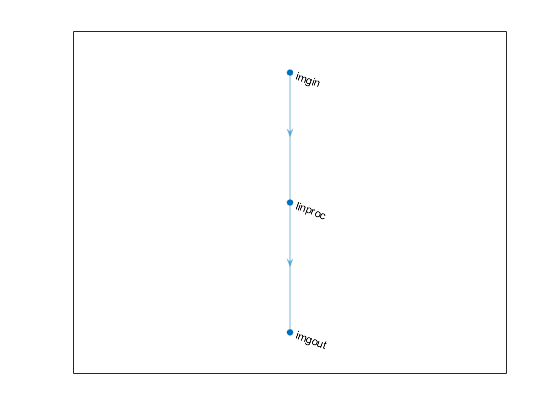

hsize = [9 9];
hsigma = 2;
downfactor = [2 2];
padopt = 'circ';
fwdproclayer = forwardMeasurement2dLayer(...
    'Name','linproc',...
    'Sigma',hsigma,...
    'PsfSize',hsize,...
    'PadOption',padopt,...
    'DecimationFactor',downfactor);
adjproclayer = fwdproclayer.createAdjointLayer();

% Simulation 
proclgraph = layerGraph();
proclgraph = proclgraph.addLayers([ ...
    imageInputLayer(size(u),'Name','imgin','Normalization','none'),...
    fwdproclayer,...
    regressionLayer('Name','imgout')]);
plot(proclgraph)

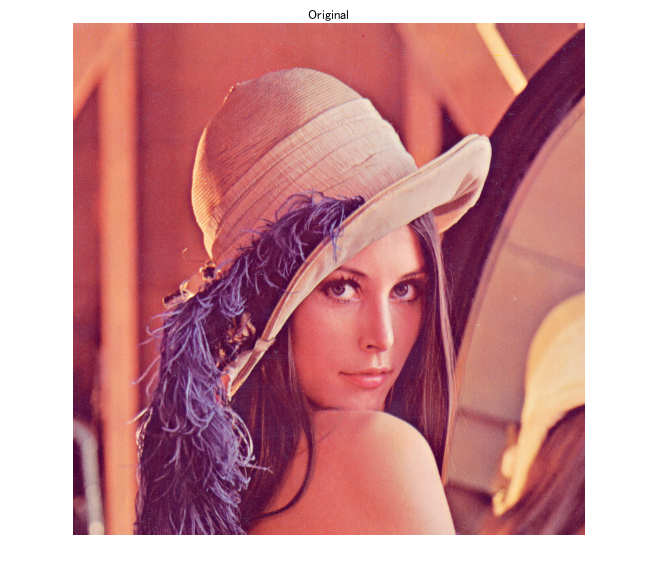

procnet = assembleNetwork(proclgraph);
v = imnoise(procnet.predict(u),'gaussian',0,sgm^2);

%
imshow(u)
title('Original')

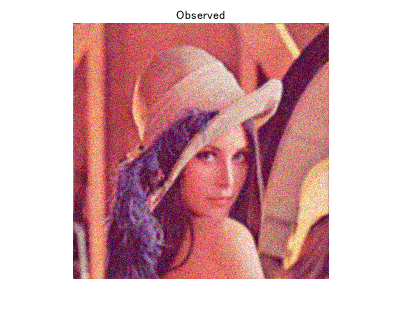

imshow(v)
title('Observed')

### Learned ISTA with Structured Convolutional Dictionary

#### References

- K. Gregor and Y. LeCun, "Learning fast approximations of sparse coding", *Proc. Int. Conf. Machine Learning*, pp. 399-406, 2010.

- V. Monga, Y. Li and Y. C. Eldar, "Algorithm Unrolling: Interpretable, Efficient Deep Learning for Signal and Image Processing," in IEEE Signal Processing Magazine, vol. 38, no. 2, pp. 18-44, March 2021, doi: 10.1109/MSP.2020.3016905.

- MATLAB SaivDr Package: [https://github.com/msiplab/SaivDr](https://github.com/msiplab/SaivDr)

- S. Muramatsu, K. Furuya and N. Yuki, "Multidimensional Nonseparable Oversampled Lapped Transforms: Theory and Design," in IEEE Transactions on Signal Processing, vol. 65, no. 5, pp. 1251-1264, 1 March1, 2017, doi: 10.1109/TSP.2016.2633240.

- S. Muramatsu, T. Kobayashi, M. Hiki and H. Kikuchi, "Boundary Operation of 2-D Nonseparable Linear-Phase Paraunitary Filter Banks," in IEEE Transactions on Image Processing, vol. 21, no. 4, pp. 2314-2318, April 2012, doi: 10.1109/TIP.2011.2181527.

- S. Muramatsu, M. Ishii and Z. Chen, "Efficient parameter optimization for example-based design of nonseparable oversampled lapped transform," 2016 IEEE International Conference on Image Processing (ICIP), Phoenix, AZ, 2016, pp. 3618-3622, doi: 10.1109/ICIP.2016.7533034.

- Furuya, K., Hara, S., Seino, K., & Muramatsu, S. (2016). Boundary operation of 2D non-separable oversampled lapped transforms. *APSIPA Transactions on Signal and Information Processing, 5*, E9. doi:10.1017/ATSIP.2016.3.

#### Problem setting:

    
$$\{\hat{\mathbf{\theta}},\{ \hat{\mathbf{s}}_n \}\}=\arg\min_{\{\mathbf{\theta},\{\mathbf{s}_n\}\}}\frac{1}{2S}\sum_{n=1}^{S}\left(\|\mathbf{v}_n-\mathbf{D}_{\mathbf{\theta}}\hat{\mathbf{s}}_n\|_2^2,\ +\lambda\|\mathbf{s}_n\|_1\right),$$$


where $\mathbf{D}_{\mathbf{\theta}}$ is a dictionary with the design parameter vector $\mathbf{\theta}}$.

#### ISTA

- Initialization: $\mathbf{s}^{(0)}$, $t\leftarrow 0$

- Proximal gradient descent: $\mathbf{s}^{(t+1)}\leftarrow \mathcal{T}_{\gamma \lambda}\left( \mathbf{s}^{(t)}-\gamma\nabla_\mathbf{s}f(\mathbf{s}^{(t)})\right)$

- If a stopping critera is satisfied then finish, otherwise $t\rightarrow t+1$ and go to Step 2.

where

- 
$$\nabla_\mathbf{s}f(\mathbf{s})=\mathbf{D}_{\mathbf{\theta}}^T\mathbf{P}^T(\mathbf{PD_{\mathbf{\theta}}\mathbf{s}-\mathbf{v})$$


- 
$$\mathcal{T}_{\gamma\lambda}(\mathbf{s})=\mathrm{sign}(\mathbf{s})\odot\max(\mathrm{abs}(\mathbf{s})-\gamma\lambda\mathbf{1},\mathbf{0})$$


- $\gamma<2/\beta$: Step size

- $\beta$: Lipschitz constant of $\nabla f$, where $\beta = (\sigma_{\mathrm{max}}(\mathbf{PD}))^2$

Step 2 of the ISTA can be written as follows

- 
$$\mathbf{s}^{(t+1)}\leftarrow \mathcal{T}_{\gamma g}\left(\mathbf{s}^{(t)}-\gamma\mathbf{D}_{\mathbf{\theta}}^T\mathbf{P}^T(\mathbf{PD}_{\mathbf{\theta}}\mathbf{s}^{(t)}-\mathbf{v})\right)$$


The above steps can equivalently be rewritten as a form of analysis, thresholding, and synthesis as follows.

#### Analysis-synthesis view of ISTA 

- Initialization: $\mathbf{s}^{(0)}$, $\mathbf{u}^{(0)}\leftarrow \mathbf{D}_{\mathbf{\theta}}\mathbf{s}^{(0)}$, $t\leftarrow 0$

- Residual: $\mathbf{r}^{(t)}\leftarrow \mathbf{P}^T(\mathbf{P}\mathbf{u}^{(t)}-\mathbf{v})$

- Analysis process: $\mathbf{y}^{(t)}\leftarrow \mathbf{D}_{\mathbf{\theta}}^T\mathbf{r}^{(t)}$

- Proximal gradient descent: $\mathbf{s}^{(t+1)}\leftarrow \mathcal{T}_{\gamma \lambda}\left(\mathbf{s}^{(t)}-\gamma\mathbf{y}^{(t)}\right)$

- Synthesis process: $\mathbf{u}^{(t+1)}\leftarrow \mathbf{D}_{\mathbf{\theta}}\mathbf{s}^{(t+1)}$

- If a stopping critera is satisfied then finish, otherwise $t\rightarrow t+1$ and go to Step 2.

The initialization part is set as

- 
$$\mathbf{s}^{(0)}\leftarrow \mathbf{D}^T_{\mathbf{\theta}}\mathbf{P}^T\mathbf{v}\Rightarrow\mathbf{u}^{(0)}\leftarrow \mathbf{P}^T\mathbf{v}$$


## Construction of layers

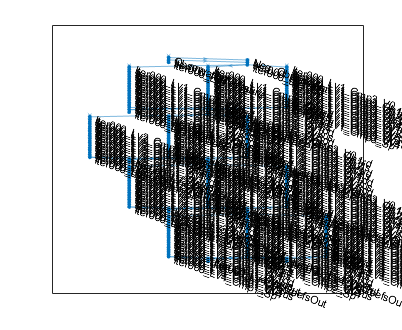

import saivdr.dcnn.*
nComponents = szPatchTrn(3);

% Parameter settings for step size
H = fftn(fwdproclayer.psf,2.^nextpow2([size(u,1) size(u,2)]));
beta = max(abs(H(:)).^2); % λmax(PP.')
gamma = 2./(beta+1e-2);

% Initialize
strIter = sprintf('Iter%03d_',0);
listalgraph = fcn_creatensoltlgraph2d([],...
    'AppendInOutLayers',false,...
    'NumberOfComponents',nComponents,...
    'NumberOfChannels',nChannels,...
    'DecimationFactor',decFactor,...
    'PolyPhaseOrder',ppOrder,...
    'NumberOfLevels',nLevels,...
    'NumberOfVanishingMoments',noDcLeakage,...
    'Mode','Analyzer',...
    'Prefix',strIter);
imginputlayer0 = imageInputLayer(szPatchTrn./[downfactor 1],'Name','Observation','Normalization','none');
adjproclayer0 = adjproclayer;
adjproclayer0.Name = [strIter 'AdjMeasure'];
listalgraph = listalgraph.addLayers(...
    [imginputlayer0,adjproclayer0]);
%
strLv = sprintf('Lv%0d_',1);
listalgraph = listalgraph.connectLayers([strIter 'AdjMeasure'],[strIter strLv 'In']);

% Add intermediate result output
listalgraph = listalgraph.addLayers(nsoltIdentityLayer('Name',[strIter strLv 'Out']));
listalgraph = listalgraph.connectLayers([strIter 'AdjMeasure'],[strIter strLv 'Out']);

% Add Coefs. output
strLv = sprintf('Lv%0d_',nLevels);
listalgraph = listalgraph.addLayers(nsoltIdentityLayer('Name',[strIter strLv 'DcCoefsOut']));
listalgraph = listalgraph.connectLayers([strIter strLv 'DcOut'],[strIter strLv 'DcCoefsOut']);
for iLv = nLevels:-1:1
    strLv = sprintf('Lv%0d_',iLv);
    listalgraph = listalgraph.addLayers(nsoltIdentityLayer('Name',[strIter strLv 'AcCoefsOut']));
    listalgraph = listalgraph.connectLayers([strIter strLv 'AcOut'],[strIter strLv 'AcCoefsOut']);
end

% Add negative process
listalgraph = listalgraph.addLayers(negativeLayer('Name','Neg_Observation'));
listalgraph = listalgraph.connectLayers('Observation','Neg_Observation');

% Plot
plot(listalgraph)

import saivdr.dcnn.*
nComponents = szPatchTrn(3);
% Iteration
for iter = 1:nIters
    strIter = sprintf('Iter%03d_',iter);
    strIterPre = sprintf('Iter%03d_',iter-1);
    
    % Analysis-synthesis system
    listalgraph = fcn_creatensoltlgraph2d(listalgraph,...    
        'AppendInOutLayers',false,...
        'NumberOfComponents',nComponents,...
        'NumberOfChannels',nChannels,...
        'DecimationFactor',decFactor,...
        'PolyPhaseOrder',ppOrder,...
        'NumberOfLevels',nLevels,...
        'NumberOfVanishingMoments',noDcLeakage,...
        'Prefix',strIter);

    % Measurement processes
    fwdproclayeri = fwdproclayer;
    fwdproclayeri.Name = [strIter 'FwdMeasure'];
    adjproclayeri = adjproclayer;
    adjproclayeri.Name = [strIter 'AdjMeasure'];
    listalgraph = listalgraph.addLayers([fwdproclayeri,additionLayer(2,'Name',[strIter 'Residual']),adjproclayeri]);
    listalgraph = listalgraph.connectLayers([strIter 'AdjMeasure'],[strIter 'Lv1_In']);

    % Analyzer
    strLv = sprintf('Lv%0d_',1);
    listalgraph = listalgraph.replaceLayer([strIter strLv 'In'],...
        learnableScalingLayer('Name',[strIter strLv 'In'],'Scale',-gamma));

    % For DC
    strLv = sprintf('Lv%0d_',nLevels);
    listalgraph = listalgraph.disconnectLayers([strIter strLv 'DcOut'],[strIter strLv 'DcIn']);
    listalgraph = listalgraph.addLayers(nsoltIdentityLayer('Name',[strIter strLv 'DcCoefsIn']));
    listalgraph = listalgraph.addLayers(additionLayer(2,'Name',[strIter strLv 'DcCoefsResidual']));
    listalgraph = listalgraph.connectLayers([strIter strLv 'DcOut'],[strIter strLv 'DcCoefsResidual/in1']);
    listalgraph = listalgraph.connectLayers([strIter strLv 'DcCoefsIn'],[strIter strLv 'DcCoefsResidual/in2']);
    listalgraph = listalgraph.connectLayers([strIter strLv 'DcCoefsResidual'],[strIter strLv 'DcIn']);
    % For AC
    for iLv = nLevels:-1:1
        strLv = sprintf('Lv%0d_',iLv);
        listalgraph = listalgraph.disconnectLayers([strIter strLv 'AcOut'],[strIter strLv 'AcIn']);
        listalgraph = listalgraph.addLayers(nsoltIdentityLayer('Name',[strIter strLv 'AcCoefsIn']));
        listalgraph = listalgraph.addLayers(additionLayer(2,'Name',[strIter strLv 'AcCoefsResidual']));
        listalgraph = listalgraph.connectLayers([strIter strLv 'AcOut'],[strIter strLv 'AcCoefsResidual/in1']);
        listalgraph = listalgraph.connectLayers([strIter strLv 'AcCoefsIn'],[strIter strLv 'AcCoefsResidual/in2']);
    end

    % Synthesizer
    strLvPre = '';
    % For DC
    strLv = sprintf('Lv%0d_',nLevels);
    if iter < nIters
        listalgraph = listalgraph.addLayers(nsoltIdentityLayer('Name',[strIter strLv 'DcCoefsOut']));
        listalgraph = listalgraph.connectLayers([strIter strLv 'DcCoefsResidual'],[strIter strLv 'DcCoefsOut']);
    end
    % For AC
    for iLv = nLevels:-1:1
        strLv = sprintf('Lv%0d_',iLv);
        % For AC
        if isLET
            if iLv == nLevels
                listalgraph = listalgraph.addLayers(...
                    letLayer('Name',[strIter strLv 'AcTh'],'Sigma',sigma,... % Activation function for AC between Analyzer & Synthesizer
                    'IsInterScale',false,...
                    'NumberOfChannels',nComponents*(sum(nChannels)-1)));
                listalgraph = listalgraph.connectLayers([strIter strLv 'AcCoefsResidual'],[strIter strLv 'AcTh']);
            else
                listalgraph = listalgraph.addLayers(...
                    letLayer('Name',[strIter strLv 'AcTh'],'Sigma',sigma,... % Activation function for AC between Analyzer & Synthesizer
                    'IsInterScale',true,...
                    'NumberOfChannels',nComponents*(sum(nChannels)-1)));
                listalgraph = listalgraph.connectLayers([strIter strLvPre 'AcTh'],[strIter strLv 'AcTh/parent']);
                listalgraph = listalgraph.connectLayers([strIter strLv 'AcCoefsResidual'],[strIter strLv 'AcTh/child']);
            end
        else % Soft-thresholding
            listalgraph = listalgraph.addLayers(...
                sfthLayer('Name',[strIter strLv 'AcTh'],'Lambda',lambda,... % Activation function for AC between Analyzer & Synthesizer
                'NumberOfChannels',nComponents*(sum(nChannels)-1)));
            listalgraph = listalgraph.connectLayers([strIter strLv 'AcCoefsResidual'],[strIter strLv 'AcTh']);
        end
        listalgraph = listalgraph.connectLayers([strIter strLv 'AcTh'],[strIter strLv 'AcIn']);
        %
        if iter < nIters
            listalgraph = listalgraph.addLayers(nsoltIdentityLayer('Name',[strIter strLv 'AcCoefsOut']));
            listalgraph = listalgraph.connectLayers([strIter strLv 'AcTh'],[strIter strLv 'AcCoefsOut']);
        end
        %
        strLvPre = strLv;
    end
    
    % Connect iteration stages
    listalgraph = listalgraph.connectLayers([strIterPre 'Lv1_Out'],[strIter 'FwdMeasure']);
    listalgraph = listalgraph.connectLayers('Neg_Observation',[strIter 'Residual/in2']);
    %
    strLv = sprintf('Lv%0d_',nLevels);
    listalgraph = listalgraph.connectLayers([strIterPre strLv 'DcCoefsOut'],[strIter strLv 'DcCoefsIn']);
    for iLv = nLevels:-1:1
        strLv = sprintf('Lv%0d_',iLv);
        listalgraph = listalgraph.connectLayers([strIterPre strLv 'AcCoefsOut'],[strIter strLv 'AcCoefsIn']);
    end
end
%plot(listalgraph)

% Output
strIter = sprintf('Iter%03d_',nIters);
listalgraph = listalgraph.addLayers(regressionLayer('Name','Restoration'));
listalgraph = listalgraph.connectLayers([strIter 'Lv1_Out'],'Restoration');

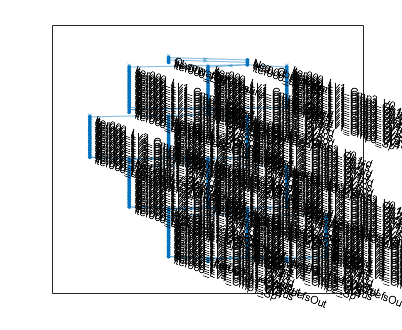

% Check
analyzeNetwork(listalgraph);

### Preparation of traning image

Randomly extracting patches from the image data store

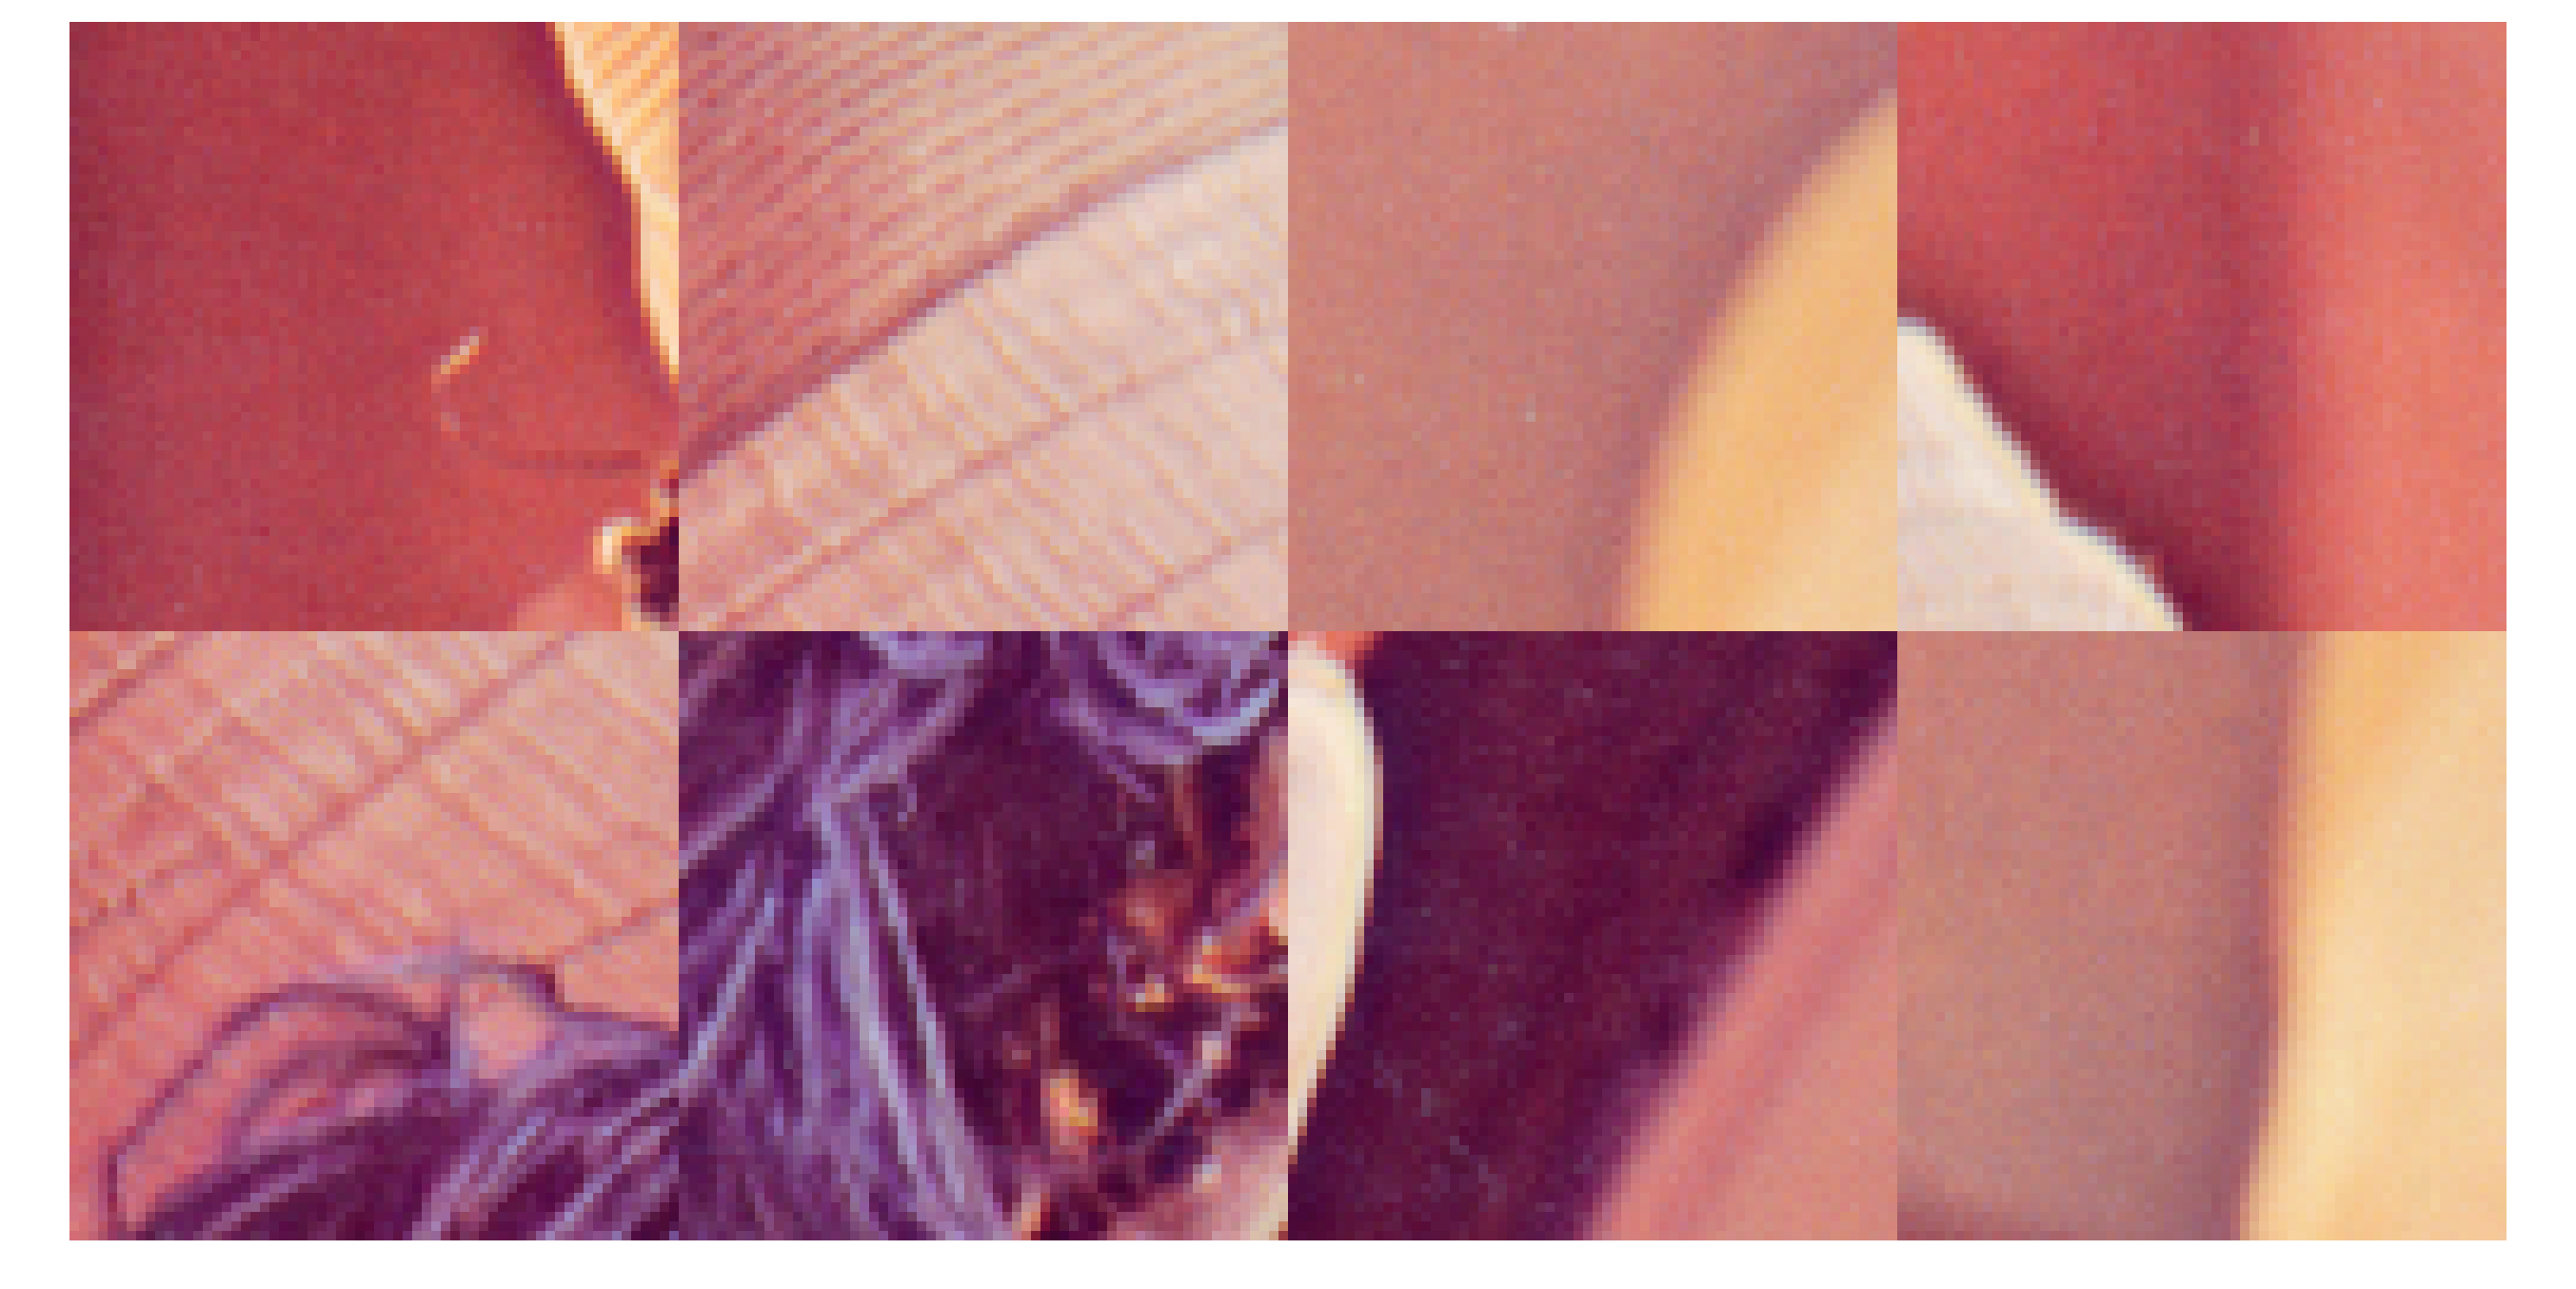

imds = imageDatastore("./data/lena.png","ReadFcn",@(x) im2single(imread(x)));
patchds = randomPatchExtractionDatastore(imds,imds,szPatchTrn,'PatchesPerImage',nSubImgs);
minibatch = preview(patchds);
responses = minibatch.ResponseImage;
montage(responses,'Size',[2 4]);

## Preperation of data set

proclgraph = layerGraph();
proclgraph = proclgraph.addLayers([ ...
    imageInputLayer(szPatchTrn./[downfactor 1],'Name','imgin','Normalization','none'),...
    fwdproclayer]);
procnet = dlnetwork(proclgraph);
obsds = transform(patchds, @(x) myobservation(x,procnet,sgm));

## Training options

opts = trainingOptions('sgdm', ... % Stochastic gradient descent w/ momentum
    ...'Momentum', 0.9000,...
    'InitialLearnRate',initialLearnRate,...
    ...'LearnRateScheduleSettings','none',...
    'L2Regularization',0.0,...1.0000e-04,... % Set zero since parameters are rotaion angles.
    ...'GradientThresholdMethod','l2norm',...
    ...'GradientThreshold',Inf,...
    'MaxEpochs',maxEpochs,...30,...
    'MiniBatchSize',miniBatchSize,...128,...
    'Verbose',1,...
    'VerboseFrequency',32,...50,...
    ...'ValidationData',[],...
    ...'ValidationFrequency',50,...
    ...'ValidationPatience',Inf,...
    ...'Shuffle','once',...
    ...'CheckpointPath','',...
    ...'ExecutionEnvironment','auto',...
    ...'WorkerLoad',[],...
    ...'OutputFcn',[],...
    'Plots','training-progress',...
    ...'SequenceLength','longest',...
    ...'SequencePaddingValue',0,...
    ...'SequencePaddingDirection','right',...
    ...'DispatchInBackground',0,...
    'ResetInputNormalization',0);...1

## Parameter initialization

listalgraph = listalgraph.removeLayers('Restoration');
listanet = dlnetwork(listalgraph);

% Initialize parameters
nLearnables = height(listanet.Learnables);
for iLearnable = 1:nLearnables
    if listanet.Learnables.Parameter(iLearnable)=="Angles"
        layerName = listanet.Learnables.Layer(iLearnable);
        listanet.Learnables.Value(iLearnable) = ...
            cellfun(@(x) x+stdInitAng*randn(size(x)), ...
            listanet.Learnables.Value(iLearnable),'UniformOutput',false);
    end
end

% Set learn rate factor & L2 factor
 for iLearnable = 1:nLearnables
     layerName = listanet.Learnables.Layer(iLearnable);
     parameterName = listanet.Learnables.Parameter(iLearnable);
     if parameterName == "Angles"
         listanet = listanet.setLearnRateFactor(layerName,"Angles",factor4angles);
         listanet = listanet.setL2Factor(layerName,"Angles",l2factor4angles);
     elseif parameterName == "Sigma"
         listanet = listanet.setLearnRateFactor(layerName,"Sigma",factor4sigma);
         listanet = listanet.setL2Factor(layerName,"Sigma",l2factor4sigma);
     elseif parameterName == "Lambda"
         listanet = listanet.setLearnRateFactor(layerName,"Lambda",factor4lambda);
         listanet = listanet.setL2Factor(layerName,"Lambda",l2factor4lambda);
     elseif ~isempty(regexp(layerName,'^Iter\d+_Lv\d+_In$','once')) && parameterName == "Scale" % gamma
         listanet = listanet.setLearnRateFactor(layerName,"Scale",factor4gamma);
         listanet = listanet.setL2Factor(layerName,"Scale",l2factor4gamma);
     elseif parameterName == "a1"
         listanet = listanet.setLearnRateFactor(layerName,"a1",factor4a1);
     elseif parameterName == "a2"
         listanet = listanet.setLearnRateFactor(layerName,"a2",factor4a2);
     elseif parameterName == "b1"
         listanet = listanet.setLearnRateFactor(layerName,"b1",factor4b1);
     elseif parameterName == "b2"
         listanet = listanet.setLearnRateFactor(layerName,"b2",factor4b2);
    end
end

### Learn rate factor

nParams = 0;
for iLearnable = 1:nLearnables
    layerName = listanet.Learnables.Layer(iLearnable);
    parameterName = listanet.Learnables.Parameter(iLearnable);
    learnRateFactor = listanet.getLearnRateFactor(layerName,parameterName);
    disp(parameterName + "@" + layerName + ": " + learnRateFactor);
    if learnRateFactor > 0
        value = listanet.Learnables.Value(iLearnable);
        nParams = nParams + numel(value{1});
    end
end

Angles@Iter000_Lv1_Cmp1_V0: 1
Angles@Iter000_Lv1_Cmp1_Vh1: 1
Angles@Iter000_Lv1_Cmp1_Vh2: 1
Angles@Iter000_Lv1_Cmp1_Vh3: 1
Angles@Iter000_Lv1_Cmp1_Vh4: 1
Angles@Iter000_Lv1_Cmp1_Vv1: 1
Angles@Iter000_Lv1_Cmp1_Vv2: 1
Angles@Iter000_Lv1_Cmp1_Vv3: 1
Angles@Iter000_Lv1_Cmp1_Vv4: 1
Angles@Iter000_Lv1_Cmp2_V0: 1
Angles@Iter000_Lv1_Cmp2_Vh1: 1
Angles@Iter000_Lv1_Cmp2_Vh2: 1
Angles@Iter000_Lv1_Cmp2_Vh3: 1
Angles@Iter000_Lv1_Cmp2_Vh4: 1
Angles@Iter000_Lv1_Cmp2_Vv1: 1
Angles@Iter000_Lv1_Cmp2_Vv2: 1
Angles@Iter000_Lv1_Cmp2_Vv3: 1
Angles@Iter000_Lv1_Cmp2_Vv4: 1
Angles@Iter000_Lv1_Cmp3_V0: 1
Angles@Iter000_Lv1_Cmp3_Vh1: 1
Angles@Iter000_Lv1_Cmp3_Vh2: 1
Angles@Iter000_Lv1_Cmp3_Vh3: 1
Angles@Iter000_Lv1_Cmp3_Vh4: 1
Angles@Iter000_Lv1_Cmp3_Vv1: 1
Angles@Iter000_Lv1_Cmp3_Vv2: 1
Angles@Iter000_Lv1_Cmp3_Vv3: 1
Angles@Iter000_Lv1_Cmp3_Vv4: 1
Angles@Iter000_Lv2_Cmp1_V0: 1
Angles@Iter000_Lv2_Cmp1_Vh1: 1
Angles@Iter000_Lv2_Cmp1_Vh2: 1
Angles@Iter000_Lv2_Cmp1_Vh3: 1
Angles@Iter000_Lv2_Cmp1_Vh4: 1
Angles@Iter0

disp("# of Parameters: = " + nParams)

# of Parameters: = 41465


NOTE: The above number excludes frozen parameters, whose learn rate factors are set to zero.

### L2 factor

for iLearnable = 1:nLearnables
    layerName = listanet.Learnables.Layer(iLearnable);
    parameterName = listanet.Learnables.Parameter(iLearnable);
    disp(parameterName + "@" + layerName + ": " + listanet.getL2Factor(layerName,parameterName))
end

Angles@Iter000_Lv1_Cmp1_V0: 1
Angles@Iter000_Lv1_Cmp1_Vh1: 1
Angles@Iter000_Lv1_Cmp1_Vh2: 1
Angles@Iter000_Lv1_Cmp1_Vh3: 1
Angles@Iter000_Lv1_Cmp1_Vh4: 1
Angles@Iter000_Lv1_Cmp1_Vv1: 1
Angles@Iter000_Lv1_Cmp1_Vv2: 1
Angles@Iter000_Lv1_Cmp1_Vv3: 1
Angles@Iter000_Lv1_Cmp1_Vv4: 1
Angles@Iter000_Lv1_Cmp2_V0: 1
Angles@Iter000_Lv1_Cmp2_Vh1: 1
Angles@Iter000_Lv1_Cmp2_Vh2: 1
Angles@Iter000_Lv1_Cmp2_Vh3: 1
Angles@Iter000_Lv1_Cmp2_Vh4: 1
Angles@Iter000_Lv1_Cmp2_Vv1: 1
Angles@Iter000_Lv1_Cmp2_Vv2: 1
Angles@Iter000_Lv1_Cmp2_Vv3: 1
Angles@Iter000_Lv1_Cmp2_Vv4: 1
Angles@Iter000_Lv1_Cmp3_V0: 1
Angles@Iter000_Lv1_Cmp3_Vh1: 1
Angles@Iter000_Lv1_Cmp3_Vh2: 1
Angles@Iter000_Lv1_Cmp3_Vh3: 1
Angles@Iter000_Lv1_Cmp3_Vh4: 1
Angles@Iter000_Lv1_Cmp3_Vv1: 1
Angles@Iter000_Lv1_Cmp3_Vv2: 1
Angles@Iter000_Lv1_Cmp3_Vv3: 1
Angles@Iter000_Lv1_Cmp3_Vv4: 1
Angles@Iter000_Lv2_Cmp1_V0: 1
Angles@Iter000_Lv2_Cmp1_Vh1: 1
Angles@Iter000_Lv2_Cmp1_Vh2: 1
Angles@Iter000_Lv2_Cmp1_Vh3: 1
Angles@Iter000_Lv2_Cmp1_Vh4: 1
Angles@Iter0

##  Training

単一の GPU で学習中。
｜＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝｜
｜　　エポック　　｜　　反復　　｜　　　　　経過時間　　　　　｜　　ミニバッチ　ＲＭＳＥ　　｜　　ミニバッチ損失　　｜　　基本学習率　　｜
｜　　　　　　　　｜　　　　　　｜　　（ｈｈ：ｍｍ：ｓｓ）　　｜　　　　　　　　　　　　　　｜　　　　　　　　　　　｜　　　　　　　　　｜
｜＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝｜
｜　　　　　　１　｜　　　　１　｜　　　　　００：０２：４６　｜　　　　　　　　１５．２７　｜　　　　　１１６．６　｜　　０．０１００　｜
｜　　　　　　８　｜　　　３２　｜　　　　　０２：３３：１９　｜　　　　　　　　　６．７４　｜　　　　　　２２．７　｜　　０．０１００　｜
｜　　　　　１６　｜　　　６４　｜　　　　　０５：０７：２１　｜　　　　　　　　　６．０２　｜　　　　　　１８．１　｜　　０．０１００　｜
｜＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝｜


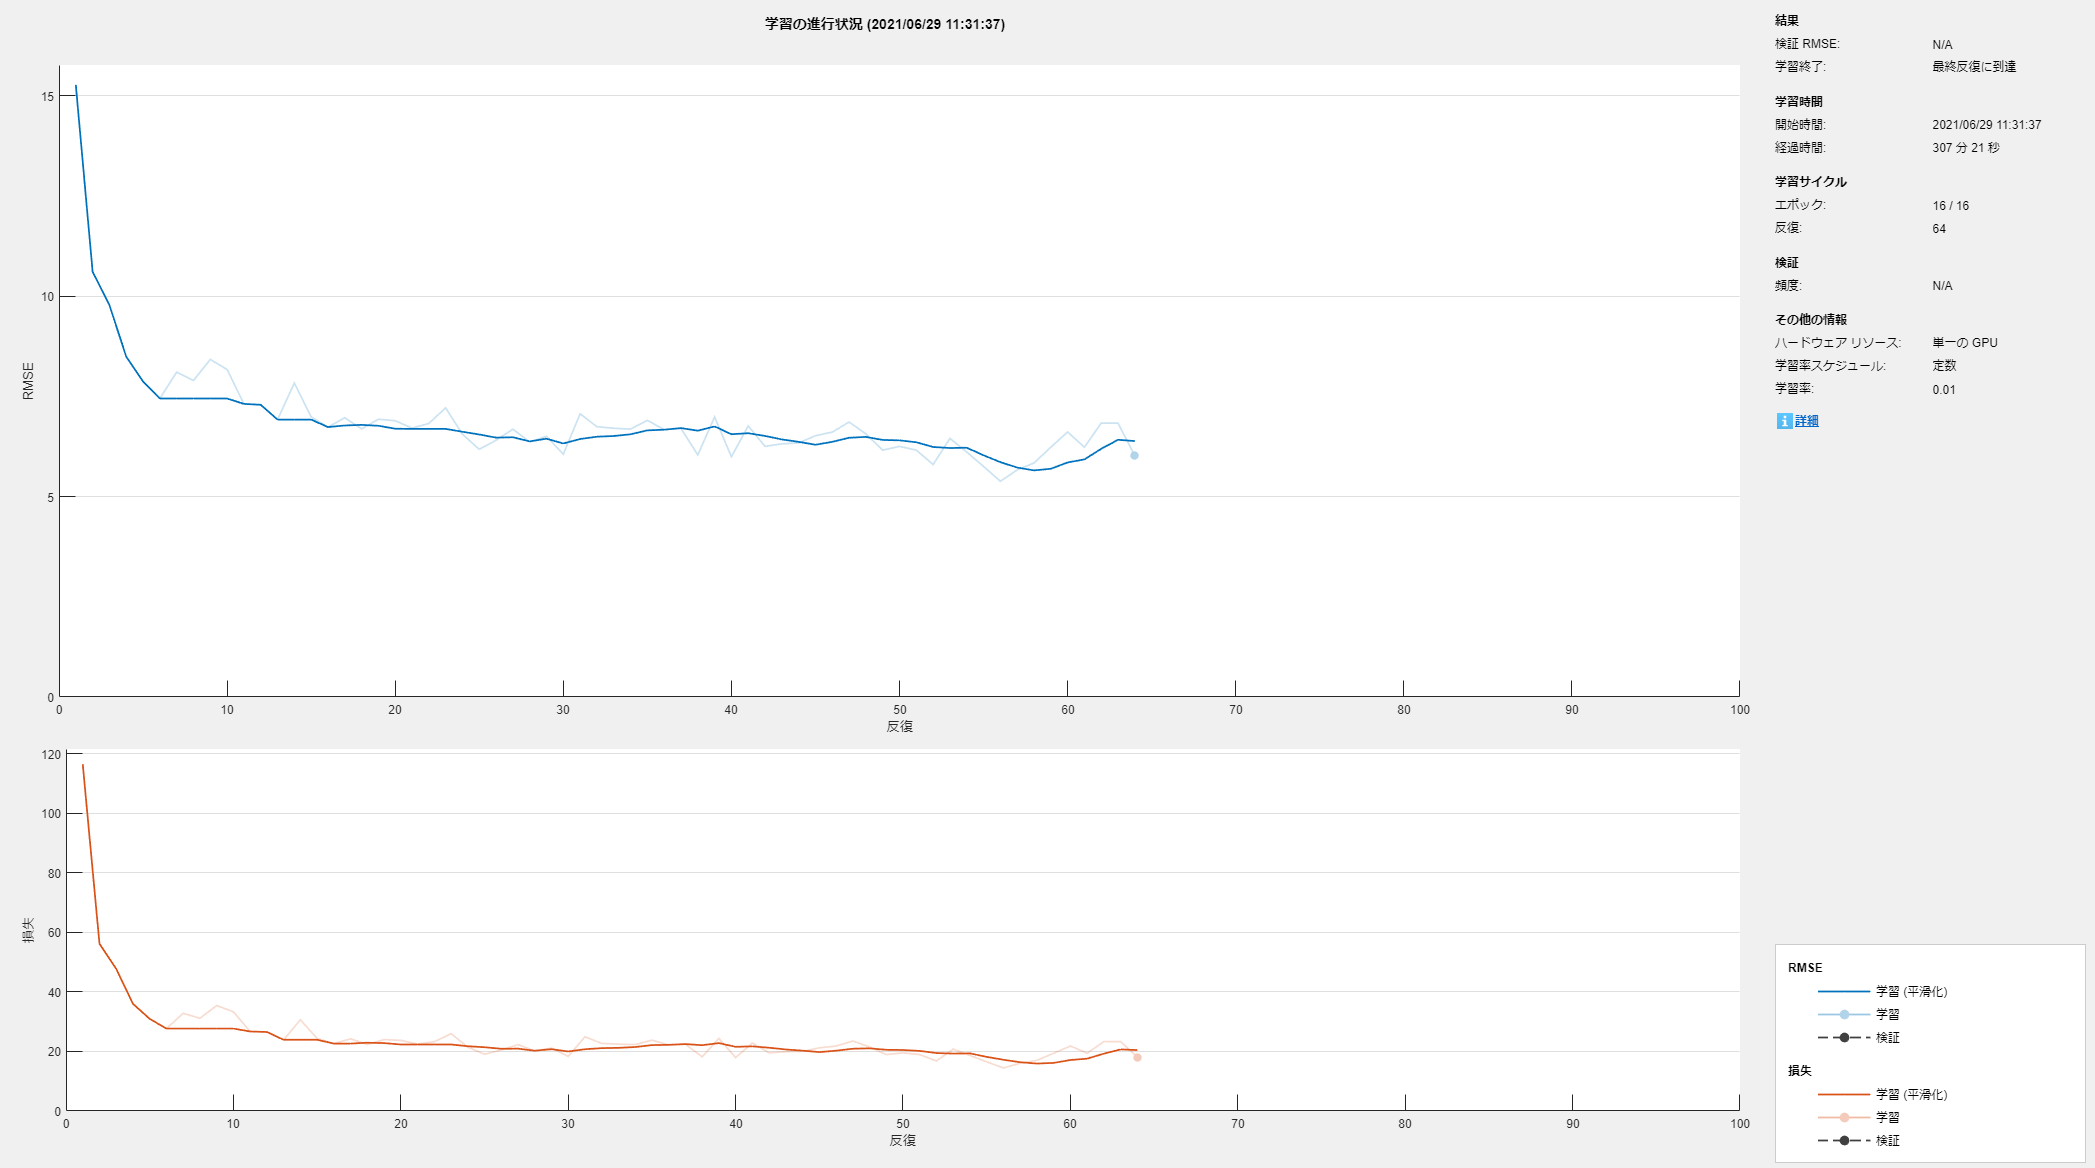

listalgraph = layerGraph(listanet); 
strIter = sprintf('Iter%03d_',nIters);
listalgraph = listalgraph.addLayers(regressionLayer('Name','Restoration'));
listalgraph = listalgraph.connectLayers([strIter 'Lv1_Out'],'Restoration');
profile on
trainednet = trainNetwork(obsds,listalgraph,opts);

profile off
profile viewer
save(sprintf('./data/nosoltlista_%s',datetime('now','Format','yyyyMMddhhmmssSSS')),'trainednet')

## Bicubic interpolation

For the sake of reference, the result with the bicubic interpolation is shown.

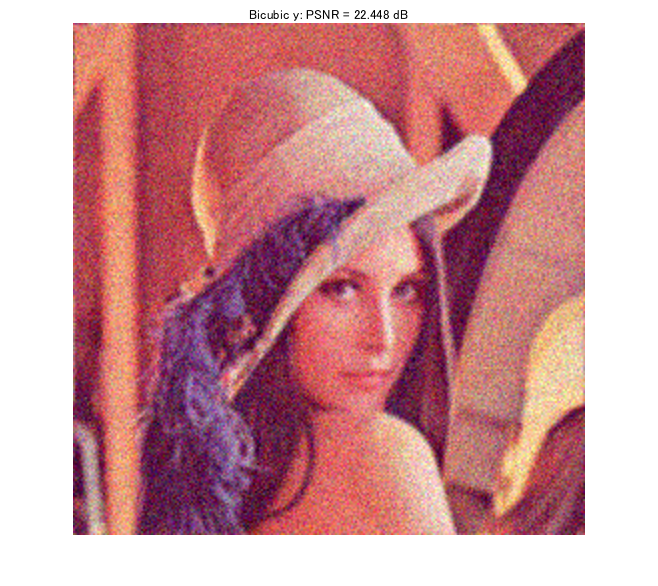

% Bicubic
y = imresize(v,2,'bicubic');
imshow(y)
title(['Bicubic y: PSNR = ' num2str(psnr(u,im2double(y))) ' dB']);

## Reconstruction by LISTA

Restoration by the trained network.

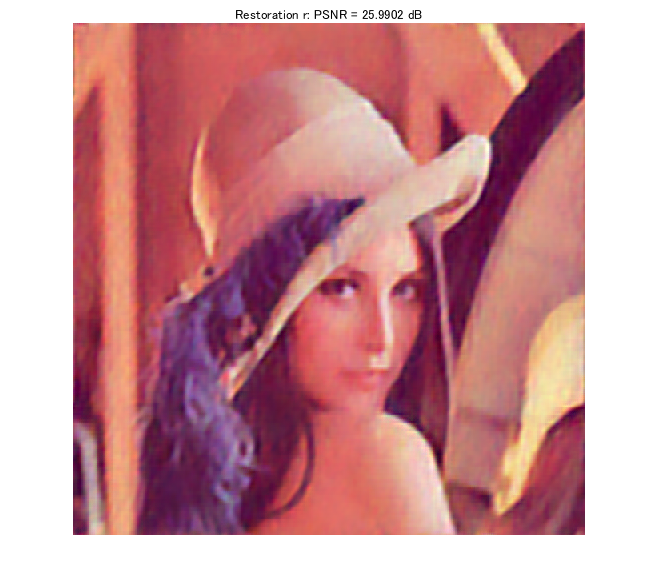

% Assemble LISTA
trainedlgraph = layerGraph(trainednet);
trainedlgraph = trainedlgraph.replaceLayer('Observation',...
    imageInputLayer(size(v),'Name','Image imput','Normalization','none'));
trainednet4predict = assembleNetwork(trainedlgraph);

% Process by LISTA
r = trainednet4predict.predict(v);
imshow(r)
title(['Restoration r: PSNR = ' num2str(psnr(u,im2double(r))) ' dB']);

## Learned parameters

trainedlgraph = layerGraph(trainednet);
trainedlgraph = trainedlgraph.removeLayers('Restoration');
trainednet = dlnetwork(trainedlgraph);

for iLearnable = 1:nLearnables
   learnables = trainednet.Learnables;
   disp(learnables.Parameter(iLearnable)+"@"+learnables.Layer(iLearnable)+":")
   disp(cell2mat(trainednet.Learnables.Value(iLearnable)))
end

Angles@Iter000_Lv1_Cmp1_V0:


  56×1 single dlarray

   -0.2119
   -0.0518
   -0.1842
    0.5710
   -0.0232
    0.4604
    0.2201
    0.2177
   -0.2624
   -0.0091
   -0.1736
    0.8491
   -0.7781
   -0.0164
   -0.4600
    0.0081
    0.1743
    0.3226
   -0.1331
   -0.5317
   -0.3413
   -0.7020
    0.6887
   -0.4011
    0.5066
    0.1002
   -0.8940
    0.0299
   -0.2781
    0.3463
    0.7864
   -0.8207
    0.5990
    0.1096
    0.3542
   -0.1401
   -0.3791
   -0.3914
    0.5986
   -0.8209
   -0.7600
    0.0533
    0.3144
    0.5569
    0.2488
   -0.0040
    0.6461
   -0.1846
    0.7876
    0.2398
    0.7381
    0.3755
    0.9928
   -1.0918
    0.0228
   -0.1925

  56×1 single dlarray



Angles@Iter000_Lv1_Cmp1_Vh1:


  28×1 single dlarray

   -0.0793
   -0.0356
    0.6299
    0.5407
   -0.9874
    0.2132
   -1.0856
    0.6650
    1.2642
    0.2135
    0.5230
   -0.3358
   -0.8541
    0.8890
    0.8096
   -0.3736
    0.3873
    0.7068
   -0.6833
    0.0579
   -0.6141
    0.5317
    0.1294
    0.0796
   -0.2676
    0.7459
   -0.1790
    0.4080



Angles@Iter000_Lv1_Cmp1_Vh2:


  28×1 single dlarray

   -0.2781
   -0.9937
    0.4483
    0.8248
    0.0954
    0.1825
   -0.1056
    0.0098
    0.0077
   -0.7450
   -0.5792
   -0.3641
   -1.1069
    0.3982
   -0.0543
    0.9632
   -0.2920
    0.4807
   -0.1233
    0.6789
   -0.3309
   -0.5146
   -0.0297
    0.8535
    0.8614
   -0.3385
    0.1588
    0.1288



Angles@Iter000_Lv1_Cmp1_Vh3:


  28×1 single dlarray

    0.9952
   -0.6760
   -0.6084
    0.4994
   -0.1381
    0.5872
   -0.8018
   -0.1169
   -0.6321
    0.5929
    0.7050
    0.1864
   -0.4086
    0.9154
   -0.3444
    0.9372
   -0.6959
   -1.0193
   -0.0764
    0.3395
   -0.4132
    0.7716
    0.2700
    0.1448
   -0.1743
   -0.2074
   -0.0698
    0.7815



Angles@Iter000_Lv1_Cmp1_Vh4:


  28×1 single dlarray

    0.3851
    0.4554
    0.7909
   -0.2299
    0.2936
   -0.4202
    0.1756
    0.3876
   -0.6891
   -1.0430
   -0.5381
   -0.1551
   -0.1572
    0.0870
   -0.1582
    0.3888
   -0.7706
    0.5099
    0.4714
    0.2920
   -0.1894
   -0.6155
   -1.1595
    0.5593
   -0.6435
   -0.3937
    0.3725
    0.1341



Angles@Iter000_Lv1_Cmp1_Vv1:


  28×1 single dlarray

    0.4276
   -0.6760
    0.1126
    0.3644
    0.5118
   -0.0646
    0.1954
    0.5850
    0.3926
    0.5804
   -0.0203
   -0.1295
    0.3484
    0.1969
   -0.1641
    0.2927
   -1.0320
    0.3473
   -0.4121
    0.2939
   -0.1808
    0.0539
   -0.1961
    0.3286
   -0.6257
   -0.0396
   -0.0553
   -0.4022



Angles@Iter000_Lv1_Cmp1_Vv2:


  28×1 single dlarray

    0.6439
   -0.1490
   -0.1829
   -0.0218
   -0.1321
   -0.9832
   -0.1913
    0.2813
    0.4833
   -0.9057
   -0.8197
   -0.3130
    0.0273
   -0.5962
   -0.2925
    0.4586
    0.4238
    0.0669
    0.0896
   -0.2562
    0.1854
   -0.6426
   -1.2791
   -0.2321
   -0.3956
   -0.3926
   -0.0019
   -0.3807



Angles@Iter000_Lv1_Cmp1_Vv3:


  28×1 single dlarray

    0.1279
    0.1811
   -0.1277
   -0.2999
    0.4592
    0.1533
   -0.4340
    0.6547
    0.2437
   -0.7514
    0.7342
   -0.3463
   -0.3976
   -1.0095
   -1.1126
   -0.1172
    0.2141
    0.5385
   -0.4965
    0.3328
   -0.3523
    0.3269
    0.6684
    0.1365
   -0.4334
   -0.3425
    0.0404
   -0.5201



Angles@Iter000_Lv1_Cmp1_Vv4:


  28×1 single dlarray

    0.2861
   -0.2552
   -0.2343
   -0.0867
   -0.3693
    0.6291
    0.9330
   -0.8796
    0.3408
   -0.7410
   -0.1606
    1.0247
   -0.1277
   -0.3102
    0.2860
   -0.0997
   -0.3519
   -0.2184
    0.0962
    0.4607
   -0.6074
   -0.3035
    1.0448
    0.4875
    0.8832
    0.0867
    0.6986
   -0.6380



Angles@Iter000_Lv1_Cmp2_V0:


  56×1 single dlarray

    0.5607
   -0.1002
   -1.0536
   -0.5763
    0.7285
   -0.6915
    0.6745
   -0.0608
    0.0701
    0.5642
    0.7627
   -0.0733
    0.4888
   -0.5710
   -0.0115
    0.1345
   -0.1834
    0.3995
    0.2754
   -0.8158
   -0.6458
   -0.2163
   -0.7807
   -0.0142
    0.3828
    0.3135
    0.8205
   -0.8932
    0.5976
   -0.5049
   -0.5202
    0.7417
   -0.6142
   -0.4412
    0.5226
   -0.4997
   -0.2104
   -1.0770
   -0.6494
   -1.7672
   -1.1536
    0.1498
   -0.2634
    0.4328
    0.8732
    0.3017
    0.6896
    0.8841
   -0.5199
    0.8765
   -0.1115
    0.0116
    0.4335
   -0.0036
    0.2441
    0.5719

  56×1 single dlarray



Angles@Iter000_Lv1_Cmp2_Vh1:


  28×1 single dlarray

   -0.3669
    0.2226
    0.4207
   -0.7381
    0.5306
    0.1159
   -0.1206
   -0.3880
    0.1588
   -0.2914
    0.5827
    0.7213
    0.4840
    1.1169
    0.3952
   -0.5499
    0.4873
   -0.3279
    0.0574
    0.4543
   -0.5770
    0.4405
    0.2239
    0.2105
    0.6573
    0.5792
   -0.5555
    0.0737



Angles@Iter000_Lv1_Cmp2_Vh2:


  28×1 single dlarray

    0.9270
   -0.0472
   -0.0476
    0.8922
    1.2212
   -0.5450
    0.1664
   -0.3875
   -0.9820
    0.2940
   -0.2278
   -0.2063
   -0.2456
   -0.4412
   -0.8269
   -0.9238
    0.1255
   -0.7522
   -0.5857
   -0.4265
   -1.5069
    0.3270
    1.0945
    0.1555
   -0.4852
    0.0435
   -0.4429
   -0.4143



Angles@Iter000_Lv1_Cmp2_Vh3:


  28×1 single dlarray

    0.0159
   -0.3480
    0.2055
    0.6421
    1.4812
   -0.4506
   -0.3168
   -0.0462
    0.7412
   -0.0493
    0.1253
    0.8597
   -0.6230
   -0.2727
    0.1667
   -0.2540
   -1.5138
   -0.6352
    0.2440
   -0.5282
    0.2113
   -0.1418
    0.0513
   -0.0547
    0.0361
   -0.3761
    0.9400
    0.3072



Angles@Iter000_Lv1_Cmp2_Vh4:


  28×1 single dlarray

    0.5591
    0.0424
   -0.3919
    0.0817
    0.4993
   -0.0258
    0.0063
   -0.6434
   -0.8967
    0.1190
    0.2239
    0.1480
    0.3021
   -0.1776
    0.4121
   -1.0639
   -0.9026
    0.3347
    1.1083
   -1.3056
   -0.3968
   -0.1801
    0.5344
   -0.0680
   -0.6710
    0.1908
    0.4902
   -0.1956



Angles@Iter000_Lv1_Cmp2_Vv1:


  28×1 single dlarray

   -0.0458
    0.1906
   -0.0760
   -0.3161
    0.2778
    0.3571
   -0.0221
    0.7571
   -0.2952
   -1.3247
   -0.0818
    0.2483
    0.3530
   -1.8206
    0.4217
   -0.1805
   -0.1884
   -1.3078
   -0.7941
    0.6620
    0.3048
    0.1828
    0.0425
   -0.7658
   -0.6191
    0.0165
    0.0387
   -0.5154



Angles@Iter000_Lv1_Cmp2_Vv2:


  28×1 single dlarray

   -0.1525
   -0.4155
   -0.0179
    0.0341
    0.1779
    0.2693
    0.4449
    0.9121
   -0.0263
    0.4373
    0.3251
    0.1242
    0.0317
    0.4448
   -0.4419
   -1.1117
    0.0109
   -0.1139
   -0.8335
    0.9816
   -0.4292
    0.3931
    0.1033
    0.3711
   -0.3463
   -0.2420
   -0.8311
    0.0911



Angles@Iter000_Lv1_Cmp2_Vv3:


  28×1 single dlarray

   -0.9329
   -0.4268
    0.8123
    0.4028
   -0.8698
    0.7669
   -0.7372
    0.4787
   -1.0834
   -0.1853
    0.6679
    0.1747
   -0.3241
   -0.2973
    0.1289
   -0.9847
   -0.7691
    0.3934
    0.0750
    0.8396
   -0.7110
   -0.0794
   -0.0161
    1.2994
   -0.4879
   -0.9007
    0.2479
   -0.2074



Angles@Iter000_Lv1_Cmp2_Vv4:


  28×1 single dlarray

   -0.1276
   -0.2555
    0.4968
    0.0454
   -0.3169
    0.3987
   -0.8558
    0.8763
   -0.6201
    0.8695
    0.8185
   -0.4567
   -0.2035
    0.3003
   -0.3130
   -1.0746
    0.2486
    0.5574
    0.4863
    0.0543
    0.2227
    0.3177
    0.9057
    0.2708
   -0.3872
    0.1821
   -0.2383
    1.4339



Angles@Iter000_Lv1_Cmp3_V0:


  56×1 single dlarray

   -1.0523
    0.6710
    0.1602
   -0.3541
    0.0379
    0.0501
    1.0392
   -0.7373
   -0.0017
    0.4042
   -0.9483
    0.0601
   -0.2504
    0.8057
    0.7412
    0.2002
   -0.0066
    0.6545
    1.0450
   -0.0925
   -0.6989
    1.0930
    0.5390
    0.5437
    0.7022
    0.7353
   -0.1280
   -0.1934
    0.5281
    0.6224
    0.7195
    0.6615
    0.3131
   -0.7848
    0.1616
   -0.3958
    0.1828
   -0.2672
    0.2743
    0.6323
    0.6612
    0.4677
    1.0217
    0.3810
    0.4964
   -0.2009
   -0.5032
    0.0179
   -0.1066
   -0.8205
   -0.3851
    0.6070
    0.5150
    0.1883
    0.2259
    0.1329

  56×1 single dlarray



Angles@Iter000_Lv1_Cmp3_Vh1:


  28×1 single dlarray

   -0.6728
    0.2144
    0.2833
    0.2525
    0.4435
    0.2414
   -1.2170
   -0.3491
   -0.0638
   -0.1220
   -0.4517
    0.5921
   -0.2156
   -0.1220
   -0.0313
    0.7779
    0.3917
   -1.3065
   -0.3539
   -0.1864
    0.9316
    0.2299
   -0.2689
    0.4022
   -0.3552
   -0.1862
    0.5079
    0.4480



Angles@Iter000_Lv1_Cmp3_Vh2:


  28×1 single dlarray

   -0.6544
    0.1923
   -0.3691
    0.5570
    0.4133
    0.2480
   -0.5432
    0.2742
    0.3500
   -0.4744
    1.3161
   -1.2730
   -0.5233
    0.4871
    0.4678
    0.3476
   -0.5134
   -0.0449
   -0.0069
   -0.2622
   -0.5644
    0.7233
   -0.5376
    0.3916
    0.3436
   -1.0603
    0.3305
    0.1322



Angles@Iter000_Lv1_Cmp3_Vh3:


  28×1 single dlarray

    0.9451
    0.9410
   -0.0401
    0.2521
    0.3603
    0.1513
    0.2195
   -0.0754
   -0.1316
    0.7976
   -0.1668
    0.1293
    0.5294
    0.8172
    1.2256
   -0.6760
    0.5444
    0.1187
   -0.4461
   -0.4104
    0.2209
   -0.6080
    0.6322
   -0.8658
   -0.7221
    0.0341
   -0.7738
    0.3365



Angles@Iter000_Lv1_Cmp3_Vh4:


  28×1 single dlarray

   -1.1791
    0.2607
   -1.2998
   -0.2768
    1.1405
   -0.2274
    0.2598
   -0.4972
   -0.6657
    0.5355
   -0.2194
   -0.0835
   -0.1025
    0.4039
   -0.5287
    0.0445
   -0.1609
   -0.8903
   -0.0380
   -0.1706
    1.1786
   -0.2216
   -0.3763
   -0.1766
   -0.8720
    0.6509
   -0.7019
    0.6294



Angles@Iter000_Lv1_Cmp3_Vv1:


  28×1 single dlarray

   -0.0910
    0.3479
    0.3913
   -0.7243
    0.6278
    0.2639
    0.0236
    0.9557
   -0.1526
   -0.3761
   -0.1034
    0.2739
   -0.0549
   -0.0623
   -0.5623
   -1.2123
   -0.1756
    0.3912
    0.0228
   -0.7215
   -0.2235
   -0.3281
    0.1809
   -0.0218
    0.1062
   -1.3056
    0.0027
    0.0805



Angles@Iter000_Lv1_Cmp3_Vv2:


  28×1 single dlarray

    0.3855
   -0.2878
    0.4837
    0.5789
   -1.0707
    0.1206
   -0.4828
    0.2829
   -0.0386
    0.9283
    0.6840
   -0.1715
    0.7490
   -0.0016
    1.6103
   -0.5470
    0.5957
   -0.8552
   -0.5066
   -0.2194
    1.1134
    0.0278
   -0.4398
    0.3248
   -0.9506
    0.2652
   -1.5902
   -0.2458



Angles@Iter000_Lv1_Cmp3_Vv3:


  28×1 single dlarray

    1.3878
   -0.4908
   -1.3292
    0.1642
   -0.1937
   -0.6033
   -0.3896
    0.2855
    0.6302
   -0.1870
   -0.4187
   -0.1168
    1.1282
    0.4033
   -0.2009
   -0.0478
   -0.6984
    0.0624
    0.8093
   -0.0264
    0.4065
    0.9151
   -0.0985
   -0.0973
    0.1161
    0.6130
    0.5794
   -0.2884



Angles@Iter000_Lv1_Cmp3_Vv4:


  28×1 single dlarray

   -0.0168
    0.6808
   -0.3110
    0.3965
    0.3024
   -0.4065
   -0.5579
   -0.5498
   -0.4036
    0.0967
   -0.4015
   -0.6637
    0.1905
   -0.7815
    0.3165
    0.0291
   -0.2709
    0.2401
    0.4125
    0.4869
    0.5151
   -0.0839
   -0.0154
    0.5141
   -0.3290
   -0.1200
   -0.3328
   -0.3683



Angles@Iter000_Lv2_Cmp1_V0:


  56×1 single dlarray

    0.5854
    0.3164
   -0.1470
   -0.8900
   -0.3850
   -0.0918
    0.0606
    0.5469
   -0.1851
   -0.0884
    0.5026
    0.1383
    0.2528
   -1.0084
    0.2047
   -0.3923
    0.4374
    0.0780
    0.1404
    0.5340
    0.6692
    0.6939
   -0.4580
   -0.0933
   -0.9830
   -0.3941
    1.0708
    0.0497
   -0.4542
   -0.7726
    0.0643
   -0.5184
   -1.3368
    0.2673
   -0.6823
   -0.7100
    0.5162
    0.6663
   -0.2425
    0.3174
    0.6869
   -0.1139
   -0.0177
    0.8803
   -0.4784
   -0.2695
    0.0463
    0.5035
    0.0230
   -0.2234
   -0.8663
    0.4154
    1.3444
    0.0307
   -0.3703
    0.1876

  56×1 single dlarray



Angles@Iter000_Lv2_Cmp1_Vh1:


  28×1 single dlarray

   -0.5462
    0.4085
    0.3063
   -0.3716
   -0.3870
   -0.7346
    0.5788
    1.3285
    0.7601
    0.0069
   -1.1509
    0.1279
   -0.1465
   -0.6993
    0.4265
    0.4240
    0.3293
    1.5516
    0.1138
   -0.0089
   -0.8267
   -0.0991
    0.8802
   -0.5376
    0.7663
    0.5692
   -0.2466
    0.2331



Angles@Iter000_Lv2_Cmp1_Vh2:


  28×1 single dlarray

   -0.8387
   -0.4008
    0.4790
    0.0764
   -0.9511
   -0.9654
    0.0656
   -0.9454
    0.3689
   -0.2453
   -0.5686
    1.4323
   -0.1354
    0.0715
   -1.0894
    0.6441
   -0.4595
   -0.1090
    0.2106
    0.2538
    0.9175
    0.1511
   -0.1530
    0.3957
    0.5364
    0.6485
    0.8028
   -0.6680



Angles@Iter000_Lv2_Cmp1_Vh3:


  28×1 single dlarray

    0.0316
   -0.5867
    0.4934
    0.3979
    0.2032
    0.5340
   -0.0960
   -0.2347
   -0.4761
   -0.3397
    0.6123
    0.5383
   -0.5328
   -0.7380
    0.2724
   -0.3318
   -0.0456
   -0.2049
    0.4038
   -0.0668
    0.5899
   -0.1732
   -0.1345
   -0.1296
    0.0691
    0.1681
    0.0448
   -0.6548



Angles@Iter000_Lv2_Cmp1_Vh4:


  28×1 single dlarray

    0.7338
    0.1573
    0.7919
   -0.6779
    0.5113
    0.7780
    0.2634
   -0.3579
    0.2077
   -0.0601
   -0.9269
    0.0148
   -0.1131
   -0.5049
   -0.5018
    0.2934
   -0.1113
   -0.1496
    0.2442
    0.6971
   -1.0132
    0.1620
    0.3344
    0.4881
   -0.4508
   -0.5420
    0.0157
   -0.4510



Angles@Iter000_Lv2_Cmp1_Vv1:


  28×1 single dlarray

    1.0840
   -0.8604
   -0.2179
   -0.0908
   -0.9716
    0.1147
   -0.6156
    0.5979
    0.3411
   -0.8918
    0.3370
    0.5465
    0.0035
   -0.2928
   -0.0117
    0.0646
   -0.8477
   -0.4228
    0.2414
    0.3912
   -0.0804
   -0.3619
   -0.4274
   -0.8620
   -0.4031
    0.7275
    0.2493
    0.6392



Angles@Iter000_Lv2_Cmp1_Vv2:


  28×1 single dlarray

    0.2924
   -0.2413
   -0.4789
   -0.3472
    0.1146
   -0.3493
   -0.5940
   -0.4190
    0.2582
    0.7333
   -0.5599
    0.4455
    0.2010
   -0.2048
    0.0220
   -0.0362
    0.3282
    0.4739
   -1.2261
   -0.3064
    0.1195
   -0.0198
   -0.2726
   -0.5287
   -0.4491
   -1.3499
    0.1130
    0.3464



Angles@Iter000_Lv2_Cmp1_Vv3:


  28×1 single dlarray

    1.2936
   -0.2925
   -0.0235
    0.3075
   -0.2317
    0.0950
   -0.1887
    0.0307
   -0.7378
   -0.7046
   -0.5075
   -0.5404
    0.6800
   -1.3190
    0.2371
    0.1051
    0.1245
    0.4800
    0.2665
   -0.4294
   -0.3065
    0.5414
    0.2986
    0.5105
    0.1647
   -0.3184
   -0.7604
    0.1643



Angles@Iter000_Lv2_Cmp1_Vv4:


  28×1 single dlarray

    0.2297
    0.5779
    0.0623
   -0.3756
   -0.6766
   -0.5748
    0.1754
   -0.3037
    0.3520
    0.9598
    0.1726
    0.0583
    0.5774
    0.1575
    0.5057
    1.3111
    0.0955
    0.4751
    0.0014
   -0.1615
   -0.1008
   -0.8295
    0.2448
    0.1474
   -1.5541
   -0.0852
    0.0722
   -0.0358



Angles@Iter000_Lv2_Cmp2_V0:


  56×1 single dlarray

   -0.3060
   -0.2920
    0.3932
   -0.0851
    0.4728
   -0.9455
    0.5518
   -0.5271
   -0.2353
   -0.4280
   -0.6777
   -0.5317
    0.1781
    0.5555
   -0.1678
   -0.0919
    0.6915
   -0.5773
   -0.6658
   -0.5419
   -0.8453
   -0.1098
   -0.5170
   -0.3993
   -0.1304
    0.3403
    0.4565
   -0.9098
    0.1468
   -0.2204
    0.4158
    0.2630
    0.5391
   -0.0032
   -0.1947
    0.5734
   -0.1357
   -1.3697
    0.5964
   -0.2581
   -0.9036
   -0.0059
   -0.2417
    1.4574
    1.2632
   -0.9038
    0.1487
    0.3007
    0.4787
    0.3008
    0.7509
    0.1641
   -0.9256
    0.8255
   -1.5753
    0.5468

  56×1 single dlarray



Angles@Iter000_Lv2_Cmp2_Vh1:


  28×1 single dlarray

   -0.2668
   -0.1137
   -0.4091
    0.0210
    0.6887
   -0.4367
   -0.5658
   -1.4991
   -0.0068
   -0.5152
    0.4705
   -0.3789
   -0.1920
   -0.0744
   -0.2325
   -0.2150
   -0.0835
    0.7048
    0.2937
   -0.2494
   -0.7654
    0.3414
   -0.0142
   -0.2568
    0.2415
   -0.6501
   -0.3432
    0.2874



Angles@Iter000_Lv2_Cmp2_Vh2:


  28×1 single dlarray

    0.1245
   -0.0453
   -0.1226
    0.3754
    0.6194
    0.3560
    0.1339
   -0.2293
   -0.0166
    0.2987
    0.4032
   -0.4434
    0.9894
   -0.0947
    0.5617
    0.6905
   -0.6161
    0.9948
   -0.3703
   -0.8211
    0.2668
   -0.6108
   -0.0639
   -0.3013
    0.0985
   -0.8254
   -0.0285
   -0.0129



Angles@Iter000_Lv2_Cmp2_Vh3:


  28×1 single dlarray

   -1.1941
    0.1853
   -0.1207
    0.3772
    0.0081
    0.2981
    0.3771
    0.1693
   -0.0149
   -0.4027
   -0.7194
   -0.0522
    0.2473
   -0.4827
    0.3526
   -0.7672
    1.2782
    0.0664
    0.6249
   -0.5491
   -0.2021
    0.0968
    0.3289
   -0.2168
    0.5445
   -0.1402
    0.0424
   -0.1706



Angles@Iter000_Lv2_Cmp2_Vh4:


  28×1 single dlarray

   -0.1530
   -0.2660
    0.3817
   -1.2446
   -0.5360
   -0.0640
    0.9808
    0.9767
   -0.1316
    0.1118
   -0.7708
    0.4078
   -0.4793
   -0.0602
    0.5117
   -0.1671
   -0.3577
    1.1301
    0.3141
   -0.2226
    0.5503
    0.1581
   -0.5755
   -0.7080
    0.3693
   -0.4246
    0.2262
    0.4968



Angles@Iter000_Lv2_Cmp2_Vv1:


  28×1 single dlarray

   -0.3678
    0.0127
   -0.1856
    0.4576
    0.1453
    0.0974
    0.6397
    1.2691
    0.0977
    0.4447
   -1.2458
    0.4378
    0.6685
   -1.2473
   -0.1061
   -0.3690
   -0.9634
   -0.9041
    0.5812
    0.7512
   -0.0025
    0.8572
   -0.4526
    0.4509
    0.3109
    0.4588
    0.7389
    0.1152



Angles@Iter000_Lv2_Cmp2_Vv2:


  28×1 single dlarray

   -0.2969
    1.0399
    0.5769
   -0.5745
   -0.6847
   -0.3762
    1.0820
    1.1381
   -0.5300
   -0.0429
   -0.7272
    0.2739
    0.7477
   -0.6044
   -0.0078
   -0.7433
    0.1687
   -0.8254
   -0.0047
    0.6217
    0.3760
    0.1179
    0.3632
    0.1376
    0.3505
    0.5969
   -0.2763
    0.4162



Angles@Iter000_Lv2_Cmp2_Vv3:


  28×1 single dlarray

    0.7452
    0.0889
    0.2533
   -0.1048
   -0.3038
   -1.3191
    0.5130
   -1.0039
    0.6072
   -0.7982
    0.4625
   -0.0528
    0.8301
   -0.7661
    0.4626
   -0.0086
    0.3605
   -0.4619
   -0.0929
   -0.7391
    0.2009
   -0.0220
    0.5706
    0.6531
    0.0234
   -0.5437
    0.1190
    0.4052



Angles@Iter000_Lv2_Cmp2_Vv4:


  28×1 single dlarray

   -0.5359
   -0.4651
   -0.4638
   -0.7106
    0.1518
   -0.4361
    0.2636
    0.4282
   -1.0325
   -0.6431
    0.6385
    0.2862
   -0.3113
   -0.3026
   -0.4424
    0.4458
   -0.1478
    0.3478
    0.2496
   -0.0817
    0.6268
    0.6162
    0.0003
    0.1334
    1.0041
    0.2431
   -0.2460
    0.1588



Angles@Iter000_Lv2_Cmp3_V0:


  56×1 single dlarray

   -0.9503
    0.7639
   -0.2369
   -0.0398
   -0.1983
   -0.0089
    0.2495
   -0.4636
    0.0670
   -0.0604
   -0.6427
    0.2040
    0.3169
    0.0468
    0.2337
    0.0098
   -0.9680
    0.5075
    0.1527
    0.9383
   -0.1405
    0.5770
   -0.4658
   -0.5830
   -0.2750
   -0.5756
    0.4482
    1.1836
    0.1901
    0.5112
   -0.6694
   -0.1867
    0.6544
    0.2566
    0.1252
    0.4154
   -0.6842
    0.0332
    0.0646
    0.0528
    0.0606
    1.0649
    0.3122
   -0.6645
   -1.0141
    0.8169
    0.0047
    0.0921
    0.6547
   -0.7324
   -0.1982
   -0.8372
    0.4127
    0.2259
   -0.3284
    0.1201

  56×1 single dlarray



Angles@Iter000_Lv2_Cmp3_Vh1:


  28×1 single dlarray

   -0.8600
   -0.0129
   -0.6377
   -0.1637
   -0.4715
   -0.6670
   -0.4602
   -0.5148
    1.0073
   -0.5412
   -0.5258
   -0.2715
   -0.9943
    0.7588
    0.3420
    1.3271
    0.0809
   -0.5418
   -1.0934
   -0.7165
    1.0335
    0.3561
   -0.2310
   -0.5746
   -0.8935
   -0.6461
    0.3872
   -0.7539



Angles@Iter000_Lv2_Cmp3_Vh2:


  28×1 single dlarray

    0.4457
    0.6555
   -0.9978
    0.1744
   -0.5625
   -0.3255
    0.8704
    0.4202
   -0.7658
    0.1938
   -0.1371
    0.2778
   -0.8314
   -0.4449
    0.2629
    0.4522
   -0.2576
   -1.2940
    0.0079
    0.2166
   -0.4123
    0.3837
    0.1971
   -0.1901
   -0.1976
   -0.5588
   -0.9899
   -0.5222



Angles@Iter000_Lv2_Cmp3_Vh3:


  28×1 single dlarray

   -0.6589
   -0.2074
   -0.1042
   -0.8944
   -0.1167
    0.9740
    0.1529
   -0.1474
   -0.6697
   -0.4854
    0.7083
    0.4592
   -0.0674
   -0.9271
    0.2869
    1.1871
   -0.2426
    0.4887
   -0.2160
   -0.3404
   -0.4322
    0.5201
   -0.2024
   -0.3344
   -0.1683
   -0.2668
   -0.5336
    0.0077



Angles@Iter000_Lv2_Cmp3_Vh4:


  28×1 single dlarray

    0.0639
   -1.1332
   -0.5711
    0.0552
   -1.0180
    0.2545
   -0.2654
    0.1340
   -0.7201
    0.4211
    0.5249
   -0.7081
   -1.5347
    0.5658
    0.2247
    0.3844
    0.5764
    1.4313
   -0.5085
    0.5048
    1.2590
   -1.0898
    1.2078
    0.0138
   -0.2825
    0.5461
   -0.3540
    0.4472



Angles@Iter000_Lv2_Cmp3_Vv1:


  28×1 single dlarray

   -0.6792
   -0.8622
   -0.0588
   -0.0095
    0.3963
   -0.8658
   -0.5355
    0.5211
   -0.5871
   -0.9276
    0.3050
   -0.0342
   -0.0603
   -0.2334
   -0.8637
   -0.6273
    0.2136
   -0.2887
    0.1344
   -0.9412
    0.1674
   -0.7670
   -0.6363
    0.5129
   -0.0245
   -0.5338
    0.2158
    0.1066



Angles@Iter000_Lv2_Cmp3_Vv2:


  28×1 single dlarray

   -1.0167
    0.2315
   -0.4430
    0.4552
   -0.0099
    0.2987
    0.9679
   -0.1557
    0.5884
    0.5399
   -0.7000
   -0.2547
   -0.1102
   -0.5975
   -0.0876
    0.4215
   -0.7272
   -0.1583
   -0.0072
    0.1726
   -0.6243
   -0.6542
    0.5530
   -0.6490
    0.5664
    0.4382
    0.6774
    0.2029



Angles@Iter000_Lv2_Cmp3_Vv3:


  28×1 single dlarray

   -0.8607
    0.6940
    0.5578
    0.8802
   -0.4059
    0.7521
   -0.2581
    0.0124
   -0.4851
   -0.6031
    1.4621
    0.1127
    0.8893
   -0.3487
    0.4170
    0.3148
    0.1968
    1.6997
   -0.0443
   -0.0844
    0.1645
    0.1516
    0.8487
   -0.5669
    0.0684
    0.3645
    0.2335
   -0.1057



Angles@Iter000_Lv2_Cmp3_Vv4:


  28×1 single dlarray

    0.7084
    0.1775
    0.1974
    0.6179
   -0.5015
   -0.3087
   -0.3670
    0.5980
    1.2411
   -0.2520
    0.4784
    0.0989
    0.2188
    0.0422
    0.3509
   -0.3164
   -0.0151
    0.0110
    0.2473
    0.9958
    0.8391
   -0.9526
   -0.3414
   -0.0266
   -0.1572
    0.5925
   -0.0379
   -0.8878



Angles@Iter000_Lv3_Cmp1_V0:


  56×1 single dlarray

   -0.0413
   -0.9033
    0.5729
   -0.5192
   -0.5047
   -0.2427
    0.8353
    0.7441
   -0.0023
    0.0813
   -0.2149
   -0.2872
   -0.5794
    0.1463
   -0.0726
    0.3899
   -0.1445
    0.2576
   -0.3745
    0.2007
    0.1676
    0.0463
   -0.1291
   -0.2910
   -0.4356
    0.1523
   -0.6973
   -0.0305
   -0.2328
    0.4255
   -0.0889
   -0.0776
    1.0925
   -0.1423
    0.4943
    0.5082
    0.2808
   -0.4570
   -0.0340
   -1.2458
   -0.5723
    0.1345
    0.2214
    0.0774
    0.5945
    0.6361
   -0.8549
    1.0328
    0.2225
   -0.4056
   -0.3166
   -1.2107
   -1.0506
   -0.8601
    0.0354
   -0.4089

  56×1 single dlarray



Angles@Iter000_Lv3_Cmp1_Vh1:


  28×1 single dlarray

   -0.9064
   -0.1756
    0.1761
   -0.2014
   -0.4062
   -0.7561
   -0.4372
   -0.0473
   -0.1005
    0.3975
    0.2740
   -1.2812
   -0.0148
   -0.3790
   -0.2061
   -0.1416
    0.1120
    0.4005
   -0.0817
    0.7062
    0.4406
   -0.1838
    0.7358
   -0.1700
   -0.4908
    0.2941
    0.2033
   -0.6674



Angles@Iter000_Lv3_Cmp1_Vh2:


  28×1 single dlarray

    0.5115
   -0.3369
   -0.6505
   -0.1532
    0.0661
    0.1335
    0.0811
   -0.7376
   -0.2983
   -0.2952
    0.2492
   -0.4726
   -0.0556
    0.2463
   -0.1833
    0.3097
   -0.7607
   -0.1921
   -0.4421
    0.1054
   -0.8765
    0.6748
   -0.4500
    0.0195
   -0.4530
   -1.0622
   -0.0544
    0.5892



Angles@Iter000_Lv3_Cmp1_Vh3:


  28×1 single dlarray

    0.1770
    1.1493
   -0.4622
   -0.4590
    0.4865
   -0.0114
    0.1298
    0.6346
   -0.6221
    0.3206
   -0.1448
    0.5008
    0.2350
   -0.2121
   -0.0441
    0.8657
    0.4656
    0.4827
   -0.8501
    0.0909
   -0.6470
    0.7082
    0.9328
    0.7149
   -0.0637
    0.3605
   -0.8652
    0.0261



Angles@Iter000_Lv3_Cmp1_Vh4:


  28×1 single dlarray

    0.0049
   -0.8566
   -0.2469
    0.3153
    0.0417
    0.3196
    0.0284
   -0.2560
   -0.0451
    0.7184
    0.0914
    0.0978
    0.4508
    0.6888
    0.0456
    0.3102
   -1.3388
   -0.4446
   -0.1949
   -0.2030
    0.4930
   -0.0126
   -0.4025
    0.3888
    0.2018
   -0.0974
    0.1073
   -1.1255



Angles@Iter000_Lv3_Cmp1_Vv1:


  28×1 single dlarray

    0.2967
   -0.0891
    0.7780
   -0.4359
    0.5617
   -0.1282
   -0.4080
   -0.5139
   -0.1130
   -0.9316
    0.1446
   -0.5909
   -0.2813
    0.0971
    0.3834
   -0.0583
   -0.2492
    1.0931
   -0.1094
    0.2550
    0.2313
    0.9573
    0.1038
    0.5721
   -0.0396
   -0.0790
    0.0495
    0.2910



Angles@Iter000_Lv3_Cmp1_Vv2:


  28×1 single dlarray

    0.0575
   -0.3145
   -0.4629
    0.2262
    0.1333
    0.1728
   -0.5144
    0.0864
   -0.0043
    0.6578
   -0.3866
   -0.7903
    0.0411
   -1.7449
   -0.5152
    0.4544
    0.3875
    0.1158
   -0.7652
    0.5465
    0.3634
    0.4994
    0.2483
   -0.3285
   -0.4763
   -0.7175
    0.8464
   -0.6256



Angles@Iter000_Lv3_Cmp1_Vv3:


  28×1 single dlarray

    0.0723
    0.1450
   -0.3514
   -0.4843
   -0.1208
   -0.3213
   -0.1410
    0.8278
    0.0231
   -0.0744
   -0.0112
   -1.1840
   -0.7717
    1.0421
   -0.0820
   -0.3558
    0.5964
   -0.2563
    0.1261
    0.1959
    0.1461
   -0.1049
   -0.6270
    0.3137
    1.1396
   -0.0718
   -0.4168
   -0.7727



Angles@Iter000_Lv3_Cmp1_Vv4:


  28×1 single dlarray

    0.9932
    0.3559
   -0.1874
    0.1541
    0.7690
   -0.8482
   -0.2630
    0.3953
    0.2115
    0.4460
   -0.0970
    0.3843
   -0.5785
    0.0990
    0.0826
   -0.3841
    0.0989
    0.3579
   -0.1882
    0.5999
    1.0735
   -1.0646
   -0.4175
    0.0705
   -0.4034
    0.7892
    0.7719
    0.0121



Angles@Iter000_Lv3_Cmp2_V0:


  56×1 single dlarray

    0.2724
    0.0835
    0.7964
    0.2388
   -0.6519
   -0.4032
   -0.7757
   -0.2847
   -0.2245
   -0.4104
   -0.0114
   -1.2123
   -0.0907
    0.0562
   -0.1841
    0.9085
   -0.2996
    0.9731
    0.0823
    0.4800
    0.1602
    0.2916
    0.2860
    0.4048
   -0.4516
   -0.6009
    0.2451
    0.0880
    0.2292
    0.0859
   -0.1190
   -0.3034
   -0.2834
    1.2130
   -0.0623
    0.1592
   -0.3905
    0.0150
   -0.2282
   -0.8675
   -0.1612
   -0.4734
   -0.5549
    1.3112
    0.1842
    0.0302
    0.1424
    1.2857
   -0.2071
   -0.7279
   -0.2515
   -0.1912
    0.6822
    0.1855
    0.1119
    0.2072

  56×1 single dlarray



Angles@Iter000_Lv3_Cmp2_Vh1:


  28×1 single dlarray

    0.6251
   -0.0336
   -0.3505
    0.0777
    1.1772
   -0.5752
   -0.0872
   -0.2535
   -0.3539
    0.0334
    0.2473
    0.1308
   -0.0575
   -0.8193
   -0.1667
   -0.8451
   -0.5865
   -1.0078
   -0.4403
    0.4618
   -0.1238
    0.2705
   -0.4299
    0.2431
    0.3527
    0.7056
   -0.6845
   -0.5656



Angles@Iter000_Lv3_Cmp2_Vh2:


  28×1 single dlarray

   -0.9079
    0.5702
   -0.4952
    0.4291
    0.8550
   -0.2245
    0.0598
   -0.5027
    0.4701
   -0.4979
   -0.3138
    0.0576
    0.1892
   -0.2353
   -0.0508
    0.2602
   -0.2242
   -0.9702
   -0.7581
    0.3941
    0.5489
    0.2291
    0.0408
    0.0180
   -0.3739
   -0.8340
   -0.6358
   -0.5345



Angles@Iter000_Lv3_Cmp2_Vh3:


  28×1 single dlarray

    0.4114
   -0.2376
    0.3622
    0.1535
    0.3216
   -0.0155
   -0.4597
    0.3140
   -0.9118
   -0.1020
    0.0321
    0.5213
    0.0036
   -0.5615
    0.0071
    0.3892
    0.2463
    0.4868
   -0.3858
    0.8294
   -0.2114
   -0.2698
    0.4689
   -0.3539
   -0.0135
    0.2272
   -0.2782
    0.3646



Angles@Iter000_Lv3_Cmp2_Vh4:


  28×1 single dlarray

    0.5631
    0.6292
   -0.1329
   -0.1355
    1.0586
    0.3849
   -0.3573
    0.7704
    0.5743
    0.3204
    0.7504
   -0.0558
   -0.5057
   -0.6203
   -0.8336
    0.6073
   -0.5097
    0.0858
    0.2893
    0.0896
    0.3349
    0.0202
   -0.1655
   -0.8456
    0.6897
    0.3292
   -0.0917
   -0.1060



Angles@Iter000_Lv3_Cmp2_Vv1:


  28×1 single dlarray

    0.2695
   -0.6449
   -0.1293
    0.3896
   -0.1911
    0.1368
    0.1106
   -0.2687
   -0.5574
    0.4314
   -0.1204
   -0.3169
   -0.1115
    0.4525
   -0.4256
   -0.4967
    0.4290
   -0.0039
   -0.4605
   -0.2744
    0.4395
    0.9325
   -0.3144
    0.7726
   -0.2764
   -0.6825
    0.7409
   -0.6584



Angles@Iter000_Lv3_Cmp2_Vv2:


  28×1 single dlarray

    0.7860
   -0.1080
   -0.3965
   -0.1693
    0.1284
    0.1389
    0.0433
    0.4719
    0.8546
   -0.3055
   -0.1814
   -0.4312
   -0.8958
   -0.2725
   -0.6481
    1.0126
   -0.4957
   -0.5687
   -1.4687
    0.3586
   -0.2559
    0.2896
   -0.1180
   -0.9135
    0.0387
    0.9169
    0.5602
    0.6762



Angles@Iter000_Lv3_Cmp2_Vv3:


  28×1 single dlarray

   -1.0323
    0.7286
   -0.6172
   -0.5484
   -0.0379
    0.2861
   -0.8560
   -0.2349
    0.4397
    0.5697
    0.3503
    1.1252
   -0.3747
   -0.1528
    0.3306
    0.0581
    0.0363
    0.4201
   -0.3487
    1.0818
    0.3241
   -0.1420
   -0.7512
    0.2975
    0.0113
   -0.5812
   -0.0135
    0.9367



Angles@Iter000_Lv3_Cmp2_Vv4:


  28×1 single dlarray

   -1.2383
    0.8052
   -0.6931
    0.7742
   -0.3359
    0.2737
    1.0827
    0.3754
    0.5981
    0.1336
   -0.2837
   -0.9539
   -0.2391
   -0.2087
   -1.0031
    0.1662
    0.2956
    0.0335
    0.0666
    0.0665
   -0.1972
   -0.1241
   -0.1675
   -0.2901
    0.3050
   -0.0024
   -0.8192
    0.3498



Angles@Iter000_Lv3_Cmp3_V0:


  56×1 single dlarray

    0.6238
    0.5160
    0.5848
   -0.3299
    0.0096
   -0.2313
    0.2056
    0.2254
    0.2019
    0.6511
   -0.4121
    0.0143
   -0.9379
    0.4980
    0.5772
   -0.8857
    0.2239
    1.0174
    0.1828
    0.7438
    0.5644
    0.5809
   -0.2403
   -0.4825
   -0.5157
    0.3524
   -1.1608
   -0.1861
    0.0591
    0.2314
   -0.1869
   -0.2884
   -0.6655
   -0.1650
   -0.5964
    0.1256
   -0.7976
    0.2565
    0.6723
    0.2719
    0.2238
   -1.1614
   -0.0274
   -0.8732
   -0.0844
   -0.5450
   -0.1959
   -0.1621
   -0.6348
    0.0883
   -0.4562
    0.6255
   -1.7323
   -0.3635
    0.1184
   -0.3432

  56×1 single dlarray



Angles@Iter000_Lv3_Cmp3_Vh1:


  28×1 single dlarray

    0.0454
    0.5475
    0.5263
   -0.3638
    0.9814
   -0.5068
   -0.6578
    0.3398
   -0.2488
   -0.5707
    0.8558
    0.0631
    0.4759
   -0.3117
   -0.5543
   -0.0059
   -0.7400
    0.0602
   -0.1414
   -0.8919
   -0.0956
    0.1465
    0.2199
    0.3794
    1.1251
    0.8910
    0.6677
   -0.8796



Angles@Iter000_Lv3_Cmp3_Vh2:


  28×1 single dlarray

   -0.1244
    0.8869
    0.3592
   -1.1709
    0.4388
   -0.5719
   -0.0906
   -0.1846
   -0.2050
    0.4901
   -0.2854
    0.2957
    0.4451
    0.7360
    0.7851
   -0.3971
   -0.8688
   -0.4519
    0.1866
   -0.1244
    0.7583
   -0.2445
    0.0347
    0.3679
    0.8475
    0.1232
   -0.6160
    0.4058



Angles@Iter000_Lv3_Cmp3_Vh3:


  28×1 single dlarray

    0.0408
    0.5501
   -0.2846
   -0.4050
    0.7602
   -0.0623
    0.0103
    0.2265
    1.1154
   -0.8250
    0.1326
    0.5902
   -0.2531
   -0.5348
   -0.0424
    0.6575
    1.0833
    0.3145
   -1.9838
    0.1890
    0.2229
    0.3913
   -0.0651
   -0.1511
    1.1719
    0.5684
   -0.7792
   -0.5033



Angles@Iter000_Lv3_Cmp3_Vh4:


  28×1 single dlarray

    0.2447
   -1.2568
   -0.6009
    0.4988
    0.1823
    0.3513
    0.3551
   -0.5334
    0.4308
   -0.0636
    0.1619
   -0.2638
    0.0137
   -0.7176
   -0.7208
   -0.2678
    0.2869
    0.6670
    0.4519
    0.1270
    0.4746
   -0.6404
   -0.2720
   -0.0839
    0.2643
    0.8374
    0.2343
   -0.3438



Angles@Iter000_Lv3_Cmp3_Vv1:


  28×1 single dlarray

   -0.5706
   -0.6052
   -0.0839
   -0.8214
    0.2855
   -0.2129
    1.0243
   -0.0261
    0.3463
    0.3418
   -0.1826
   -0.4401
    0.0805
    0.5020
   -0.4678
   -0.0311
   -0.9381
   -0.4921
   -0.3841
   -0.3618
   -0.3056
    1.1614
    0.7884
   -0.5545
    0.0651
   -0.3325
   -0.3081
    0.1127



Angles@Iter000_Lv3_Cmp3_Vv2:


  28×1 single dlarray

    0.4316
   -0.4237
   -0.2422
    0.3842
   -0.2257
   -0.4573
   -0.0810
   -0.6666
    0.5587
   -0.5169
    0.5248
   -0.5445
    0.2797
    0.5841
   -0.3831
   -0.8306
    0.2652
   -0.6340
    0.4069
   -0.6749
    0.6540
    0.6174
   -0.0232
    0.3519
    0.0985
   -0.3279
   -0.6384
    0.1478



Angles@Iter000_Lv3_Cmp3_Vv3:


  28×1 single dlarray

   -1.2787
    0.3533
    0.5541
   -0.4325
    0.4646
   -0.3846
   -0.5299
   -0.1999
   -0.1648
   -0.1242
    0.2918
   -0.4565
   -1.1993
    0.8387
   -0.7349
   -0.2591
   -0.0175
   -0.2422
    0.4848
    1.2889
    0.0753
    0.2842
    0.1716
    0.1566
    0.2637
    0.0914
    0.0904
    0.0013



Angles@Iter000_Lv3_Cmp3_Vv4:


  28×1 single dlarray

    0.6914
   -0.2439
    0.0034
   -0.3254
   -0.4763
    0.5134
   -0.6318
   -0.4211
    0.2942
   -0.6301
   -0.0860
   -0.0785
    0.3655
    0.0354
   -0.0155
    0.5338
    0.2573
   -0.2776
   -0.7338
    1.2274
    0.2572
    0.3044
   -0.0406
   -1.0892
   -0.8584
   -0.8829
   -0.3500
    0.3980



Angles@Iter000_Lv4_Cmp1_V0:


  56×1 single dlarray

   -0.5253
    0.1539
    0.7456
   -0.9190
    0.4574
    0.5087
    0.4216
    0.1132
   -0.2426
    0.1288
    0.5283
   -0.6056
   -0.1350
   -0.4878
    0.4391
    0.5726
   -0.5168
   -0.6277
    0.2791
   -0.9102
    0.6454
    0.2305
   -0.1130
   -0.0167
   -0.3366
    0.6573
    0.2128
   -0.2688
    0.8830
   -0.1583
    0.8975
   -0.1257
    0.3866
   -0.2951
   -0.6735
    0.3621
   -0.1831
   -1.1922
   -0.7677
   -0.3100
    0.6839
   -0.1753
    0.0023
    0.8075
    0.1623
   -1.0211
   -0.3250
    0.9733
   -0.9488
   -0.9546
    0.9177
   -0.5408
    0.4143
   -0.1626
   -0.5133
   -0.3920

  56×1 single dlarray



Angles@Iter000_Lv4_Cmp1_Vh1:


  28×1 single dlarray

   -0.4843
    0.6294
   -0.4309
    0.0526
    0.2771
   -0.2520
   -0.1250
   -0.3570
   -0.0349
   -0.2737
   -0.0601
    0.3155
   -0.1041
   -0.1615
    0.5381
   -0.3776
    0.7917
    0.2250
    0.7492
    0.0637
    0.5970
   -0.5854
   -0.2326
   -0.3850
    0.1951
    1.1413
   -0.3361
    0.1606



Angles@Iter000_Lv4_Cmp1_Vh2:


  28×1 single dlarray

    1.1298
   -0.8666
   -0.0651
    1.2480
   -0.4930
    0.5570
    0.3502
   -0.7537
    0.7420
    0.6654
    0.0882
   -0.3460
   -0.0694
   -0.7063
    0.6559
   -0.1544
   -0.0918
   -0.5528
   -0.2827
    0.0289
    0.3516
   -0.3640
    0.1245
   -1.0018
   -0.0295
   -1.0053
    0.2058
   -0.9813



Angles@Iter000_Lv4_Cmp1_Vh3:


  28×1 single dlarray

   -0.6292
    0.8443
   -0.0601
    0.5464
   -0.7050
    0.3978
    0.1729
   -0.0002
   -0.2275
   -0.0933
    0.0688
   -0.4365
    0.1423
   -0.1775
   -0.2729
    0.9031
   -0.2895
   -0.2932
   -0.7966
   -1.2736
    0.0403
   -0.3838
    0.6492
    0.4082
   -0.5397
    0.5413
   -0.2240
    0.1093



Angles@Iter000_Lv4_Cmp1_Vh4:


  28×1 single dlarray

    0.0042
   -0.4474
   -0.0729
    0.1699
   -0.7732
    0.0920
   -0.2007
   -0.3859
   -0.8967
    0.3784
    0.2219
   -0.7333
   -0.5997
    0.2557
   -0.1850
   -0.7963
    0.0936
   -0.7909
    0.1109
    1.2577
    0.9053
    0.5314
   -0.6240
    0.4846
   -0.6268
    0.5878
    0.1602
    0.2819



Angles@Iter000_Lv4_Cmp1_Vv1:


  28×1 single dlarray

   -0.0889
   -0.0266
    0.9708
    0.4050
   -0.2060
    0.2768
    0.2148
    0.1871
    0.4863
    0.3185
    0.6119
    0.7464
   -0.4507
    0.3628
   -0.1375
   -0.3326
    0.6653
    0.3567
    0.4667
    0.2076
   -0.6833
   -1.4897
   -0.6136
   -0.0582
    0.3105
   -0.8530
    0.4193
   -0.8536



Angles@Iter000_Lv4_Cmp1_Vv2:


  28×1 single dlarray

    0.5820
   -0.7109
    0.3450
   -0.6385
    0.6676
    0.4596
   -0.3663
    0.0831
    1.6561
   -0.4305
    0.3394
    1.2437
   -0.5221
    0.6919
   -0.1636
    0.6612
    0.0974
    0.2137
   -0.5442
   -0.1440
   -0.2339
    0.1141
    0.2305
    0.2254
   -0.2608
   -0.4293
   -0.1804
    0.3415



Angles@Iter000_Lv4_Cmp1_Vv3:


  28×1 single dlarray

    0.5389
    0.1405
   -0.3606
    0.2729
   -0.0880
    0.2003
   -0.3017
    0.0649
   -0.3582
   -0.0014
    0.9913
    0.2128
    0.2921
   -1.5704
    0.3423
   -0.6190
    0.0528
   -1.0194
   -0.2858
    0.0987
    1.3212
    0.7158
    0.5575
    1.2175
    0.2336
    0.6274
   -0.4561
   -0.3037



Angles@Iter000_Lv4_Cmp1_Vv4:


  28×1 single dlarray

    0.5013
   -0.0444
    0.0797
    0.7564
    0.0427
   -0.1232
   -0.5707
   -0.4378
   -0.5813
   -0.2230
    0.9804
    0.4345
   -0.0518
   -0.0842
   -0.0514
   -0.9491
   -0.3538
   -0.0453
    0.0495
    0.8489
    0.1871
    0.3582
   -0.0602
   -0.1838
   -0.9849
   -1.0275
    0.6021
    0.7726



Angles@Iter000_Lv4_Cmp2_V0:


  56×1 single dlarray

   -0.3794
    0.6235
   -1.1517
    0.0048
   -0.0281
   -0.2049
    0.4354
   -0.1532
   -0.5526
   -0.1762
   -1.1777
   -0.7745
   -0.5440
   -0.4947
   -0.0617
    0.9109
    0.2155
    0.4064
   -0.1964
   -0.4719
   -0.0132
    0.0675
    0.2181
   -0.6652
    0.3021
   -0.6697
   -0.6886
   -0.0338
   -0.0297
   -0.3749
    0.2599
   -0.0286
    0.1847
    0.1160
   -0.0336
   -0.7023
    0.6681
   -0.3492
   -0.1732
   -0.4977
   -0.0376
   -0.2869
    0.7044
   -0.1859
   -0.1729
    0.2096
   -0.3125
   -0.1636
   -0.3341
   -0.1109
   -0.3578
   -0.2413
    0.2435
    0.0949
    0.3214
    0.2422

  56×1 single dlarray



Angles@Iter000_Lv4_Cmp2_Vh1:


  28×1 single dlarray

    0.7045
    0.1456
    0.5447
   -0.1236
   -0.5361
   -0.2512
   -0.5808
    0.0976
    0.1654
   -0.0773
    0.6163
   -0.1410
   -0.3334
   -0.6824
    0.1600
   -0.8034
   -0.4760
    0.6972
    0.2638
    0.8521
    0.1350
   -0.3039
   -0.0726
    0.1244
    0.0238
    0.4484
    0.2643
   -0.1319



Angles@Iter000_Lv4_Cmp2_Vh2:


  28×1 single dlarray

   -0.9483
   -0.4632
   -0.3012
    0.0262
    0.2026
    0.0832
    0.1467
   -0.4222
    0.7850
   -0.1865
    0.3752
    0.2788
    0.0088
   -0.3405
   -0.2959
    1.2090
    0.5836
    0.3330
    0.3724
   -0.3972
    0.1191
    0.5221
    0.3555
    0.0695
   -1.1542
    0.6394
   -0.2499
    0.3101



Angles@Iter000_Lv4_Cmp2_Vh3:


  28×1 single dlarray

    0.4502
    0.1557
   -1.0228
   -0.1603
    0.2322
    0.1345
    0.5127
   -0.1723
    0.3428
   -1.2453
   -0.0449
    0.4121
    0.4730
   -0.2237
   -0.1945
    0.4347
    0.3532
   -0.0751
   -0.0348
    0.7252
    1.0469
   -0.6539
   -0.4707
   -0.8738
    0.5736
   -0.7803
    0.4582
   -0.6781



Angles@Iter000_Lv4_Cmp2_Vh4:


  28×1 single dlarray

    0.2378
   -0.3629
    0.1806
    0.4046
   -0.0249
   -0.1349
   -0.1468
   -0.6239
    0.1814
    0.2556
    0.3132
    0.6788
    1.0410
    0.2740
    0.0618
   -0.7223
    1.1272
   -0.6237
    0.2511
    0.7015
   -0.1226
    0.6559
   -0.8048
   -0.1108
    0.7033
   -0.7482
    0.1964
    0.2356



Angles@Iter000_Lv4_Cmp2_Vv1:


  28×1 single dlarray

    0.6439
    0.4352
   -0.0193
    0.2180
    0.0747
    0.4552
    0.2371
    0.0588
    0.0417
   -0.2529
   -0.6879
    0.5574
   -1.1268
   -0.6722
   -0.2129
    0.4808
    0.2802
    0.2016
    0.9792
   -0.0765
    0.5655
   -0.1976
   -0.9048
   -0.2076
   -0.9217
    0.2750
    0.1254
   -1.0512



Angles@Iter000_Lv4_Cmp2_Vv2:


  28×1 single dlarray

   -0.2400
    0.3892
   -0.1935
    0.2107
   -0.0237
   -0.0628
    0.0042
    0.1247
    0.4199
    0.5694
    0.1620
    0.4615
    0.3944
    0.5995
    0.4335
   -0.6643
    0.1686
    0.2369
   -0.1203
   -0.8982
    0.1386
   -0.0021
   -0.0511
    0.1667
   -0.8529
   -0.0879
   -0.5513
    0.6965



Angles@Iter000_Lv4_Cmp2_Vv3:


  28×1 single dlarray

    0.5730
    0.1867
    0.2988
    0.0648
    0.0677
   -0.2423
    1.0932
    0.1988
   -0.2442
    0.8859
    0.0015
    0.0628
   -0.4092
    0.8882
    0.0562
    0.3555
    0.2907
    0.0786
   -0.2501
    0.2748
    0.8489
   -0.2968
    0.4315
    0.1116
   -0.3594
   -0.8158
    0.3923
   -0.1050



Angles@Iter000_Lv4_Cmp2_Vv4:


  28×1 single dlarray

    0.5255
    0.4578
   -0.0908
    0.0895
   -0.3320
   -0.3916
   -0.2593
    0.0519
    0.2016
    0.1181
   -0.1495
   -0.0275
   -0.3318
   -0.3150
    0.0678
    0.4297
    0.2506
   -0.8409
    0.7138
    0.2435
    0.2599
    0.3663
   -0.3982
    0.5039
   -0.1439
    0.4728
   -0.5806
   -0.6374



Angles@Iter000_Lv4_Cmp3_V0:


  56×1 single dlarray

    0.2299
    0.8756
    0.0158
    0.5130
   -0.3884
   -1.3224
    0.1581
    0.1743
    0.2030
    0.4827
    0.6412
    0.2169
    0.5366
    0.1268
    0.5331
   -0.5611
   -0.2940
    0.1762
    0.0608
    0.1167
    0.5184
    0.2496
   -0.0347
   -0.4514
   -0.0256
   -0.2792
    0.4813
    0.0946
    0.3300
    0.3028
   -0.2156
   -0.1101
    0.8986
    0.2385
    0.5551
    0.0196
   -1.3272
   -0.1332
   -0.8778
    0.6674
    0.2442
   -0.8906
   -0.7744
    0.5934
   -0.7164
    0.4358
    0.2358
    0.0133
    0.6253
    0.3346
    0.5809
   -0.5974
    0.2381
    0.4189
   -0.6898
    0.1889

  56×1 single dlarray



Angles@Iter000_Lv4_Cmp3_Vh1:


  28×1 single dlarray

   -0.1931
    0.0022
    0.7681
    0.1339
   -0.2497
   -0.0695
    0.1263
   -0.0634
   -0.1861
    0.0300
    0.0878
   -0.1905
   -0.2443
   -0.2307
   -0.0222
    0.5848
   -0.8857
    0.7222
    1.0675
    0.0229
    0.0112
    0.9669
    0.0952
    0.2485
   -0.5887
    0.0522
   -0.7535
    0.4718



Angles@Iter000_Lv4_Cmp3_Vh2:


  28×1 single dlarray

   -0.3250
   -0.3716
    0.2224
   -0.1953
    0.1731
    0.0005
    0.1137
   -0.2479
   -0.1115
    0.5244
    0.3580
   -0.7582
   -0.3241
    0.2493
    0.0268
   -0.7810
   -1.4740
    0.0177
   -0.1974
    0.1350
   -0.0399
    0.4043
   -0.0023
    0.0659
    0.5803
   -0.1629
    0.2794
   -1.3245



Angles@Iter000_Lv4_Cmp3_Vh3:


  28×1 single dlarray

   -0.0805
    1.2222
   -1.2172
   -0.1199
    0.0784
    0.1178
   -0.2053
   -0.3766
    0.0562
   -0.3095
    0.2279
   -0.1636
    0.2681
    0.2588
    0.0749
   -0.4429
   -0.0717
   -0.2482
    0.0755
    0.3035
   -0.3240
   -0.1441
   -0.0704
   -0.8125
    1.0829
    0.0402
    0.6322
   -0.4294



Angles@Iter000_Lv4_Cmp3_Vh4:


  28×1 single dlarray

   -0.6792
    0.4688
    0.4441
   -0.6044
   -0.0270
   -0.3725
   -0.4736
   -0.2693
   -0.3377
   -0.4059
    0.3477
    0.0347
    0.0528
   -0.7361
    0.3222
   -0.6539
   -0.1885
   -0.5345
    0.2896
   -0.7991
   -0.1417
   -0.0117
   -0.4396
   -0.4267
   -0.1474
   -0.4667
   -0.9828
   -0.2212



Angles@Iter000_Lv4_Cmp3_Vv1:


  28×1 single dlarray

   -0.9020
   -1.0360
    0.4279
    0.3710
   -0.0800
    0.4061
   -0.1235
    0.1356
   -1.1497
    0.2190
    0.0561
   -0.0598
   -0.0372
   -0.5583
    0.2895
   -0.9377
    0.8637
    0.1324
    0.5444
    0.5701
    0.3061
    1.4881
    0.8633
   -0.8196
    0.0609
   -0.4079
    0.4491
    0.3711



Angles@Iter000_Lv4_Cmp3_Vv2:


  28×1 single dlarray

   -0.3326
   -0.4496
    1.2322
    0.0331
   -0.0863
    0.2731
   -0.8655
    0.2089
    0.2639
    0.0621
    0.1094
    0.1971
    0.0243
   -0.3570
   -0.2204
   -0.4853
    0.1314
    0.1030
    0.1147
   -0.6566
    0.0898
   -0.3990
   -0.6552
    0.4432
    0.1754
    0.2602
   -0.2530
    0.8739



Angles@Iter000_Lv4_Cmp3_Vv3:


  28×1 single dlarray

   -0.4017
    0.1120
   -0.1967
    0.0561
    0.2265
   -0.0220
    0.1481
    0.3729
   -0.0939
    0.1343
   -0.8584
   -0.4619
   -0.8172
   -0.0331
    0.2393
    1.5246
    0.5214
   -0.2115
    0.1131
   -0.2560
   -0.4644
    0.2754
    0.0837
   -0.6543
    0.0501
    0.0821
   -0.1551
    0.0864



Angles@Iter000_Lv4_Cmp3_Vv4:


  28×1 single dlarray

   -0.0479
    1.0167
    0.1584
    0.2659
    0.0444
    0.2801
    0.1841
    0.3094
    0.0121
   -0.0321
   -0.8474
    1.2136
   -0.8773
    0.1905
    0.0805
   -0.0351
   -0.3929
    0.7608
   -0.1055
    0.1110
    0.3544
   -0.5996
    0.1192
    0.5414
    0.2184
   -0.2391
    0.5282
    0.0404



Scale@Iter001_Lv1_In:


  1×1 single dlarray

   -2.5479



Angles@Iter001_Lv1_Cmp1_V0:


  56×1 single dlarray

    1.1981
    0.6023
   -0.6609
   -0.8240
   -0.9281
   -0.3563
   -0.1791
   -0.2429
   -0.2124
    0.5326
   -0.1103
    0.8854
    0.0846
    0.4146
    0.1805
    1.2400
   -0.2518
    0.0593
   -0.8345
    0.6350
    0.3373
    0.0466
    0.6291
    0.0280
   -0.3413
    0.0369
   -0.1394
   -0.7111
    0.5511
    0.0252
   -0.9433
   -0.3262
   -0.5588
    1.1790
   -0.4492
    0.2069
   -0.0361
   -0.2633
    0.2574
   -0.0147
    0.2855
    0.2705
   -0.6642
   -0.6887
   -0.5311
   -0.2355
    0.4181
    0.6481
    0.3525
    0.7299
   -1.1773
   -0.5968
   -0.4014
    0.4911
    0.0478
    0.6273

  56×1 single dlarray



Angles@Iter001_Lv1_Cmp1_Vh1:


  28×1 single dlarray

   -0.8229
    0.0020
   -0.2559
    0.8167
    1.3040
   -0.2147
   -0.0281
    0.1928
   -0.2310
   -0.1969
   -0.6916
    0.7138
    0.5516
   -0.1543
   -0.1018
   -0.0959
    0.5231
   -0.0872
   -0.3675
   -0.2904
    1.2881
   -0.2147
    1.5689
   -0.2215
   -1.2396
    0.9304
    0.1668
    0.1773



Angles@Iter001_Lv1_Cmp1_Vh2:


  28×1 single dlarray

    0.2375
   -0.2566
    0.6041
    0.9208
    0.4692
   -0.6089
   -0.0331
    0.0005
   -0.1121
   -0.1657
   -0.1859
   -0.0175
   -0.3892
    0.0349
    0.2899
    0.7261
    0.0809
    0.3265
   -0.1576
    0.4832
   -0.6752
    1.0296
    0.5962
   -0.1994
   -1.0856
    0.4523
    1.0968
    0.6464



Angles@Iter001_Lv1_Cmp1_Vh3:


  28×1 single dlarray

    0.0661
   -0.4486
    1.3050
    1.0646
    0.7587
    1.0419
    0.1916
   -0.3741
   -0.5132
    0.4072
    0.0229
    0.0535
   -0.1970
    0.0531
    0.4871
   -0.5645
   -0.1808
    0.1622
   -0.7470
   -0.0828
    0.1461
   -0.0771
   -0.0920
    0.5843
    0.8402
    0.5777
   -0.3004
   -0.5523



Angles@Iter001_Lv1_Cmp1_Vh4:


  28×1 single dlarray

    0.3159
   -0.9298
    0.1788
   -0.8979
   -0.6220
    0.1923
    0.6249
   -0.7552
    0.4210
    0.5142
    0.4596
    0.3648
   -0.0864
   -0.0276
   -0.5122
    0.3738
   -0.3979
   -1.0144
    0.4304
    0.3437
    0.5337
    0.3623
   -0.3140
    0.4940
   -1.0898
    0.1807
    0.1182
    0.3921



Angles@Iter001_Lv1_Cmp1_Vv1:


  28×1 single dlarray

    0.3590
   -0.1930
    0.0182
   -0.2563
    0.6685
    0.2279
    0.5025
   -1.2243
    0.3074
   -0.1617
   -0.0792
   -0.2458
    0.6092
    0.3412
    0.1191
    0.0415
   -0.9290
   -0.4526
    0.6920
    0.7853
    0.2725
   -0.3631
   -0.4640
   -0.1165
    0.2596
    0.3671
    1.3620
    0.2977



Angles@Iter001_Lv1_Cmp1_Vv2:


  28×1 single dlarray

   -0.1223
    0.2994
    0.3044
    0.2503
   -0.1312
   -1.3932
    0.1309
   -0.1664
    0.4093
   -0.0774
    0.2840
   -0.2735
   -0.4493
    0.3604
   -1.3124
   -0.2496
    0.1368
    0.0029
    0.4749
    0.0665
    0.0409
    0.2621
   -0.2754
   -0.3833
    0.5663
    0.5644
   -1.0710
    0.3578



Angles@Iter001_Lv1_Cmp1_Vv3:


  28×1 single dlarray

    0.4077
    0.8597
    0.1158
    0.1475
   -0.6833
    0.3206
    0.3450
   -0.1746
    0.0268
    0.2942
    0.3725
    0.3435
   -0.1629
    0.2341
   -0.7543
    0.3357
    0.1630
   -0.8566
    0.2417
    0.2737
    0.1680
   -0.2392
   -0.2627
   -0.2302
    0.1289
    0.1901
   -0.8224
   -0.0036



Angles@Iter001_Lv1_Cmp1_Vv4:


  28×1 single dlarray

    0.7071
   -0.1732
    0.2804
    0.1087
    0.7102
    0.0449
    0.4555
   -0.3328
   -0.0981
    0.6393
    0.3691
    0.2118
   -0.4600
   -0.7754
    0.2411
   -0.1206
   -0.4384
   -0.1213
    0.1204
   -0.6197
   -0.2862
    0.0104
    0.4041
    0.6655
    0.2662
   -0.8012
   -0.2882
    0.0210



Angles@Iter001_Lv1_Cmp2_V0:


  56×1 single dlarray

    0.0539
    0.7431
   -0.0219
    1.1173
   -0.3509
   -0.3920
    0.1217
   -0.2752
    0.8256
    0.0797
    0.4823
   -0.0622
   -0.3042
   -0.6819
   -0.3028
   -0.5244
    0.1874
    0.8302
   -0.0865
    0.5215
    0.5881
   -0.7169
   -0.0573
   -0.1713
   -0.2077
   -0.2909
   -0.9660
    0.4918
   -0.9551
    0.2426
    0.5652
    0.4019
    1.0931
   -0.0350
   -0.5792
   -0.0117
   -0.7084
   -0.2649
    0.2261
   -0.6980
    1.1351
   -0.0758
   -0.0398
    0.9079
   -0.0222
   -0.6026
   -0.1946
    0.8145
   -0.0281
    0.4320
   -0.6717
   -0.3157
   -0.4623
    0.7742
    0.1107
    0.1745

  56×1 single dlarray



Angles@Iter001_Lv1_Cmp2_Vh1:


  28×1 single dlarray

   -0.2703
   -0.4000
    0.3625
   -0.2907
    0.3246
    0.2343
    0.0095
    0.2232
    0.5353
   -0.1808
   -0.2229
    0.1195
   -0.1632
    0.2102
    0.0067
   -0.7416
    0.5312
    0.8950
    0.5819
   -0.8723
    0.0454
   -0.5643
    0.0797
   -0.7023
    1.0127
   -0.1360
   -0.7104
   -0.1264



Angles@Iter001_Lv1_Cmp2_Vh2:


  28×1 single dlarray

   -0.1011
    1.0054
    0.3039
    0.3863
    0.0999
    0.4360
    0.1994
   -0.2759
   -0.6840
    0.3476
   -0.2106
    0.1388
    0.2860
   -0.2959
   -0.3474
   -0.2984
    0.0469
   -0.0236
   -0.4982
    0.5352
   -0.2707
    0.6514
   -0.8238
   -0.8012
   -0.0178
   -0.2527
   -0.0675
    0.3270



Angles@Iter001_Lv1_Cmp2_Vh3:


  28×1 single dlarray

   -0.3958
    0.7602
   -0.4108
   -1.2337
   -0.5721
    0.2047
    0.5104
    0.9190
    1.2754
    0.0321
   -0.9411
   -0.2866
   -0.0503
   -0.4832
   -0.1602
   -0.0788
    0.2650
    0.0279
   -0.2595
    0.2104
   -0.0578
    0.2838
   -0.0298
   -0.1021
   -1.1482
    0.3771
   -0.6371
   -1.5282



Angles@Iter001_Lv1_Cmp2_Vh4:


  28×1 single dlarray

   -0.2875
   -0.8131
    0.2638
   -0.4701
    0.6032
    0.5764
    0.1142
   -0.6017
    0.1071
    0.2565
   -0.1297
   -0.2030
   -1.0904
   -0.5704
   -0.5325
   -0.7392
    0.1100
   -0.5484
    0.1086
   -0.5581
    0.0144
    0.2324
   -1.2308
    0.5598
    0.1416
   -0.7100
   -0.2363
    0.0126



Angles@Iter001_Lv1_Cmp2_Vv1:


  28×1 single dlarray

   -1.2874
   -0.0203
    0.1175
   -0.0791
    0.3964
   -0.6258
   -0.7265
    1.0082
   -0.8471
   -0.3321
    0.0690
   -0.3123
   -0.5839
    0.4720
   -0.8369
   -0.0419
    0.9208
   -0.2823
   -0.3653
   -0.2217
   -0.2700
   -0.1969
   -0.6654
    0.4888
    0.4863
    0.7238
   -1.0028
    0.3451



Angles@Iter001_Lv1_Cmp2_Vv2:


  28×1 single dlarray

   -0.1373
   -0.3034
   -0.3317
   -0.0225
   -0.2133
    0.2369
    0.8644
    0.3567
    0.7781
   -0.1610
    0.0768
   -0.3152
   -0.2029
   -0.1310
    0.7199
    0.0086
    1.1610
   -0.2011
    0.4285
   -0.3895
   -0.3939
   -0.0857
   -0.5701
    0.6288
   -0.5178
    0.1656
   -1.0795
   -0.4786



Angles@Iter001_Lv1_Cmp2_Vv3:


  28×1 single dlarray

   -0.2710
   -0.3837
   -0.3574
   -0.8669
    0.5912
   -0.1073
    0.5794
    0.2314
    0.8571
    0.7006
   -0.4439
    0.1572
    0.3032
   -0.4107
    0.0348
   -1.4827
   -0.5790
   -0.1053
    0.7772
   -0.6938
   -0.1656
    0.9772
    0.2131
   -0.7279
    0.6416
    0.8388
   -0.7241
   -0.2678



Angles@Iter001_Lv1_Cmp2_Vv4:


  28×1 single dlarray

   -0.3290
    0.3725
    0.5249
    0.2131
   -0.7595
    0.3408
   -0.3633
    0.0324
    0.2351
    0.7883
   -0.1902
    1.2297
   -0.2293
   -0.1514
    0.0022
    0.2814
   -1.5575
   -1.3003
    0.2326
   -0.7045
   -0.0109
   -0.4503
    0.1085
    0.2903
    0.2438
    0.5997
   -0.0163
   -0.3079



Angles@Iter001_Lv1_Cmp3_V0:


  56×1 single dlarray

    0.5362
   -0.6538
    0.9967
   -0.3605
   -0.2298
    0.1250
    0.5160
   -0.2656
   -0.4023
    1.2778
   -1.1451
   -0.7927
   -0.1580
   -0.4697
   -0.4527
   -0.3408
   -0.3547
   -0.3410
    0.0323
    0.3932
    0.2634
   -0.7619
   -0.2672
    0.7774
   -0.2189
   -0.1966
   -0.3185
    0.5189
   -0.3185
   -0.3804
   -0.7873
    0.0758
    0.1242
   -0.0830
   -0.2233
    0.0006
    0.1787
   -0.0251
   -0.5865
   -0.5050
   -1.2464
    0.2933
   -0.6157
    0.3152
    0.2930
   -0.3280
   -1.8602
   -0.1579
   -0.1556
   -0.4626
    0.1856
    0.7723
    0.6971
    0.4043
    0.4030
    0.9998

  56×1 single dlarray



Angles@Iter001_Lv1_Cmp3_Vh1:


  28×1 single dlarray

   -1.2912
   -0.6388
    1.2760
    0.5393
    0.7459
    0.0764
   -0.1585
   -0.1803
    0.3117
   -0.1964
   -0.4983
   -0.3007
    0.7301
   -0.2081
    0.3416
    0.1618
    0.7264
    0.4892
   -0.0659
   -0.9304
   -0.1139
   -0.1102
    0.3124
    0.6584
   -0.3443
    0.1472
   -0.6530
    0.6875



Angles@Iter001_Lv1_Cmp3_Vh2:


  28×1 single dlarray

   -0.4763
   -0.6594
    0.3723
    0.4016
   -0.0611
    0.7044
   -0.3789
    0.2386
   -1.0459
   -0.1916
    0.1822
    0.0246
   -0.7685
   -0.2976
   -0.3049
    0.5474
    0.3157
   -0.3777
   -0.6018
   -0.6259
    0.1576
    0.2672
   -0.0431
   -0.4232
   -0.0867
    0.7111
    0.2363
    0.3861



Angles@Iter001_Lv1_Cmp3_Vh3:


  28×1 single dlarray

   -0.4444
    0.5250
   -0.5887
   -0.1117
   -0.6561
    0.3930
   -0.6454
    1.4056
   -0.2234
    0.3734
   -0.2488
    0.0477
   -0.3831
   -0.0602
   -0.1100
    0.2000
    0.6245
   -0.8028
    0.4817
    0.4164
   -0.7398
   -0.1045
   -0.9432
   -0.3964
   -0.5000
   -0.4518
   -0.4212
   -0.4755



Angles@Iter001_Lv1_Cmp3_Vh4:


  28×1 single dlarray

   -0.3695
    0.4745
    1.2288
   -0.2130
   -0.8065
    0.2755
    0.2530
    0.0993
   -0.7904
   -0.5593
   -0.2155
   -0.5479
   -0.0212
    0.4222
    0.0026
   -0.3364
    0.3147
   -0.2014
   -0.5597
   -0.0346
   -0.1684
    0.2181
    0.5198
   -0.5869
   -0.0782
   -0.2123
    0.4492
    0.2546



Angles@Iter001_Lv1_Cmp3_Vv1:


  28×1 single dlarray

    0.1563
   -0.2063
   -0.2475
    0.2445
    0.2592
    0.2809
    0.4573
    0.4237
   -1.2749
    0.5326
   -0.2787
   -0.6866
   -0.6226
    0.1420
   -0.0505
   -0.1652
    0.3418
   -0.6497
    0.5176
    0.2488
    0.1325
    0.2205
   -0.6536
   -0.1876
    0.7553
    1.2305
   -0.4646
   -0.5261



Angles@Iter001_Lv1_Cmp3_Vv2:


  28×1 single dlarray

    0.2794
   -0.8602
    0.6975
    0.1300
   -0.7921
   -0.1036
   -0.4228
    0.4953
   -0.5480
   -0.2717
    0.2510
   -0.5098
    0.1681
   -0.3563
   -0.2367
    0.3118
   -0.3916
   -0.4365
   -0.7969
    0.2139
   -0.8573
    0.2310
   -0.3555
   -0.1104
   -1.0757
   -0.1686
   -0.0136
    0.1911



Angles@Iter001_Lv1_Cmp3_Vv3:


  28×1 single dlarray

   -0.1873
    0.2654
    0.2504
   -0.6074
   -0.6813
   -0.2471
    0.3217
   -0.2981
    0.4920
   -1.0734
   -0.2161
   -0.4301
    0.4663
   -0.3258
   -0.6414
   -0.9579
    0.0376
    0.3650
   -0.0707
    0.2509
   -0.2587
   -0.1516
   -0.4821
   -0.2220
   -0.5204
   -0.1323
   -0.1595
    0.4494



Angles@Iter001_Lv1_Cmp3_Vv4:


  28×1 single dlarray

   -0.6566
    0.3622
   -1.1314
    0.6078
   -0.0604
   -0.1171
    0.1940
    0.3275
    1.0034
    0.4144
    0.8264
   -0.5294
   -1.0934
    0.2546
   -0.0526
    0.1216
    0.2701
   -0.0434
   -0.8588
   -0.5779
   -0.5027
    0.0293
   -0.6949
    0.9612
    0.9385
   -0.4270
    1.0119
    0.4480



Angles@Iter001_Lv2_Cmp1_V0:


  56×1 single dlarray

    0.2732
   -0.9132
   -0.0796
   -0.7034
   -0.3612
   -0.1405
   -0.6132
    0.0187
   -0.1416
    0.1263
   -0.4477
    0.7908
   -0.1063
   -0.3926
   -0.8948
    0.1646
   -0.7020
    0.3510
    0.4108
   -0.4943
   -0.2715
   -0.6780
    0.2551
    0.7978
    0.2582
   -0.3323
    0.6512
    0.2759
   -0.0102
    0.1899
    0.7947
   -0.3402
   -0.4545
   -1.0428
   -0.4579
    0.3474
    0.7323
   -0.3959
    0.0077
   -0.5780
   -0.9157
    0.9139
   -0.6394
    0.4001
    0.3985
    0.4880
   -0.1757
    0.0416
    0.6302
    0.6466
    0.2104
    0.3200
   -1.0159
   -0.0823
   -0.1792
    0.4697

  56×1 single dlarray



Angles@Iter001_Lv2_Cmp1_Vh1:


  28×1 single dlarray

    0.1931
   -0.0419
   -0.5335
   -0.8659
   -0.3114
   -0.0971
   -0.6635
   -0.4551
   -0.0022
   -0.7233
    0.8446
    0.0527
    0.5524
   -0.1830
    0.3339
   -0.0161
   -0.2463
   -1.5932
    0.3570
   -0.4694
    0.1080
    0.0100
    0.4193
   -0.1414
   -0.3121
   -0.0500
    0.9539
    0.2273



Angles@Iter001_Lv2_Cmp1_Vh2:


  28×1 single dlarray

    0.0828
   -0.1162
   -0.1110
    0.6863
   -0.0233
    0.9863
   -0.3398
   -1.2504
    0.0151
    0.1789
    0.8481
    0.2425
    0.1170
   -0.1227
    0.3738
    0.3124
   -0.1496
    0.2230
   -0.1644
   -1.1256
    0.6631
    0.1545
    0.9307
   -0.2497
    0.5891
   -0.2774
   -0.2454
    0.5114



Angles@Iter001_Lv2_Cmp1_Vh3:


  28×1 single dlarray

    0.1194
   -0.1084
    0.2715
   -0.2122
   -0.1820
   -0.1100
   -0.6002
    0.2145
   -0.3195
   -0.1981
    0.3451
   -0.0348
   -0.2388
   -0.2813
   -0.9070
   -0.7026
    0.2922
   -0.9027
    0.0942
   -0.4559
    0.0539
   -0.2485
    1.0538
    0.8337
   -0.1789
    0.6692
    0.4818
    0.0126



Angles@Iter001_Lv2_Cmp1_Vh4:


  28×1 single dlarray

    0.2998
   -0.0680
    0.2009
    0.2141
   -0.0265
   -0.6000
    0.0846
    0.5027
   -0.4499
   -1.1918
   -0.4404
    0.6732
    0.5428
    0.4940
    0.2794
    0.0208
   -0.2051
   -0.3427
   -0.0980
   -0.3379
   -0.9829
    0.2630
   -0.6320
    0.7694
    0.0974
    0.5985
    0.1755
   -0.7232



Angles@Iter001_Lv2_Cmp1_Vv1:


  28×1 single dlarray

   -0.1638
    0.0138
   -1.3004
   -0.3774
   -1.0130
   -0.0961
    0.0524
    0.1051
   -0.3449
   -0.2010
   -0.3762
    0.1190
    0.0705
    0.1267
    0.3385
    0.6745
   -0.0811
   -0.2775
    0.4949
   -0.2523
   -0.5684
   -0.5427
   -0.5970
    0.5836
   -0.3738
   -0.8955
    0.5540
    0.9052



Angles@Iter001_Lv2_Cmp1_Vv2:


  28×1 single dlarray

   -0.0474
   -0.1396
    0.1740
   -0.3827
   -0.3834
    1.2082
    0.2446
   -0.7238
   -0.1338
   -0.6686
   -0.2577
    0.2833
    0.6995
    0.7259
   -0.0244
    1.3465
    0.3508
   -0.4190
   -0.0281
    0.8127
    0.3414
    0.0367
   -0.5321
    0.3826
    0.2124
   -0.5032
   -0.3010
    0.4035



Angles@Iter001_Lv2_Cmp1_Vv3:


  28×1 single dlarray

    0.0656
   -0.5133
   -0.1853
    0.1219
    0.4409
    0.6120
    0.1374
    0.2568
    0.0998
   -0.5248
   -0.6065
   -0.3255
    0.0368
    0.0719
   -0.1448
    0.5874
   -0.1642
   -0.1081
   -0.3892
    0.9371
   -0.6802
   -0.6313
    0.4596
   -1.0098
   -0.3590
    0.0102
   -0.3451
    0.3249



Angles@Iter001_Lv2_Cmp1_Vv4:


  28×1 single dlarray

    0.6217
    0.7201
    0.1273
   -0.7356
   -0.5887
    0.8840
   -0.6801
    0.0100
    0.6640
   -0.6050
    0.3779
   -0.9782
   -0.1340
    0.2267
   -0.0322
    0.5412
   -0.5676
   -0.1830
   -0.2171
    0.3120
   -0.0972
   -0.3586
   -0.3084
   -0.1097
    0.0916
    0.6991
   -0.8935
   -0.6042



Angles@Iter001_Lv2_Cmp2_V0:


  56×1 single dlarray

    0.1455
   -0.1762
   -0.6176
    0.4488
    0.5283
   -0.4814
   -0.6967
    0.9483
   -1.1013
    0.7845
   -0.6387
    0.5264
    0.4809
   -0.1714
   -0.0080
    0.3850
   -0.4542
    1.0078
   -0.8955
    0.2830
   -0.1512
    0.6477
    0.0003
   -0.1672
    0.7462
    0.2202
   -0.3948
    0.3646
    0.4056
    0.1027
    0.1693
   -0.3989
   -0.6951
   -0.2770
    0.0486
   -0.2218
   -0.2832
    0.0666
   -1.1175
    0.3410
    0.0292
   -0.2306
    0.9521
    0.7269
    0.0787
    0.3471
   -0.1755
   -0.1233
   -0.4048
    0.1781
   -0.9106
    0.3890
    0.3040
    0.1912
   -0.2755
   -1.0893

  56×1 single dlarray



Angles@Iter001_Lv2_Cmp2_Vh1:


  28×1 single dlarray

    0.9962
    0.2577
   -0.0911
    0.2762
   -0.2273
    0.5391
    0.0537
   -0.1626
    0.1263
    0.4165
   -0.8088
    0.3945
   -0.3928
    0.0675
   -0.5046
    0.0269
   -0.0074
   -0.8113
   -0.4288
    0.1721
    0.3053
   -1.1779
   -0.2029
    0.1490
    0.0737
   -0.2380
   -0.3004
   -0.2095



Angles@Iter001_Lv2_Cmp2_Vh2:


  28×1 single dlarray

   -0.5882
    0.1537
    0.3793
   -0.8092
    0.1347
   -0.5894
    0.0073
   -0.1925
   -0.5354
    0.5012
   -0.5291
    0.0808
   -0.5700
   -0.0775
    0.1808
   -0.1713
   -0.1764
   -0.6839
   -0.6269
   -0.1503
    0.3600
   -0.3596
    0.0530
   -0.2101
   -0.0096
    0.1540
    0.1608
   -0.0912



Angles@Iter001_Lv2_Cmp2_Vh3:


  28×1 single dlarray

   -0.3369
   -0.1664
   -0.0223
    0.2635
    0.3740
    0.3922
    0.0478
   -0.2614
    1.2302
   -0.4345
    0.0853
    0.8441
    0.6470
   -0.5659
    0.6497
   -0.7674
   -0.1221
    0.3426
    0.0539
    0.7488
    0.1771
    0.7625
    0.6087
   -0.2443
   -0.2167
   -0.5420
    0.0731
    1.1912



Angles@Iter001_Lv2_Cmp2_Vh4:


  28×1 single dlarray

    0.5713
   -0.9590
    1.4402
    0.6029
   -0.0100
   -1.0348
   -0.3284
    0.2744
   -0.2842
   -0.8438
    0.2922
   -0.4178
    0.4923
   -0.5871
   -0.7096
   -0.0254
   -0.0650
    0.2770
    0.1597
   -1.0478
    0.8431
    0.1835
    0.2142
   -0.4481
   -0.4541
    0.3560
    0.6745
   -0.0025



Angles@Iter001_Lv2_Cmp2_Vv1:


  28×1 single dlarray

    0.5772
    1.3604
   -0.1764
   -0.3136
    0.2192
   -0.3699
   -0.3220
    1.1110
   -0.5881
    0.9175
    0.0956
    0.0186
   -0.1271
   -0.6877
    0.1678
   -0.8045
    0.2803
   -0.3598
    0.2334
    0.0700
   -0.0805
    0.5953
    0.4934
    0.1434
    0.4673
    0.5781
    0.0098
    0.1435



Angles@Iter001_Lv2_Cmp2_Vv2:


  28×1 single dlarray

   -0.1591
   -0.4896
    1.1642
    0.6683
   -0.1736
    0.7269
   -0.5671
    0.0396
   -0.1653
    0.8484
    0.9843
    0.5801
   -0.1705
   -0.1402
   -0.0273
    0.8536
    0.5709
   -2.0465
    0.1914
   -0.5719
   -0.3915
    0.0468
   -0.2204
    0.4950
   -0.4883
    0.5701
   -0.2067
    0.3909



Angles@Iter001_Lv2_Cmp2_Vv3:


  28×1 single dlarray

    0.0755
   -0.1462
    0.4796
    0.0588
    0.7584
    0.2575
   -0.8100
    0.2018
    0.2318
   -0.5997
    0.6436
   -0.5901
    0.2479
   -0.1516
    0.1593
    0.5295
   -0.3369
   -0.1113
   -0.2017
   -0.0256
   -0.0340
   -0.8965
    0.5961
    0.4936
    0.1273
    0.1725
   -0.7429
    0.5270



Angles@Iter001_Lv2_Cmp2_Vv4:


  28×1 single dlarray

    0.1686
    0.2980
    0.2913
    0.4811
    0.1141
   -0.1359
    0.5289
   -1.0931
   -0.2069
    0.7631
   -0.3415
   -0.1900
    0.2752
    1.1595
    0.4074
    0.6909
    0.0224
    0.7078
   -0.6172
   -1.0204
    1.1423
    0.3653
   -0.9241
    0.4402
   -0.1397
   -0.5068
   -0.3710
    0.0008



Angles@Iter001_Lv2_Cmp3_V0:


  56×1 single dlarray

   -0.5444
    0.7462
    0.3513
    0.2526
   -0.1607
   -1.7209
    0.2475
   -0.4508
    0.4311
   -0.4763
   -0.0179
    0.7274
   -0.2022
    0.3042
    0.2751
   -0.6130
   -0.3467
    0.6152
    0.2378
    0.3533
    1.0486
    0.0399
    0.6427
   -0.2722
    0.5916
    0.7494
   -0.1885
   -0.6102
   -0.7472
   -0.6920
    0.2916
   -0.0830
    0.0549
    0.2701
    0.3278
    0.0920
   -0.6063
   -0.1802
   -0.9286
   -0.1984
   -0.1203
    0.3076
    0.0571
    0.7451
    0.0855
   -0.4944
   -0.4902
    0.0751
   -0.5425
   -0.4860
   -0.7047
    0.3640
    0.5263
    0.1460
   -0.5563
    0.7863

  56×1 single dlarray



Angles@Iter001_Lv2_Cmp3_Vh1:


  28×1 single dlarray

    0.0880
    0.7616
    0.7448
    0.9728
    0.3487
   -0.2297
    0.1510
    0.6146
   -0.3297
   -1.3382
   -0.5424
   -0.3604
    0.2377
    0.0785
   -0.8331
    0.4022
    0.3286
   -0.0920
    0.1931
   -0.3685
   -0.2716
   -0.1498
    0.6973
   -0.5293
   -0.6707
    0.3601
   -1.3519
   -0.4254



Angles@Iter001_Lv2_Cmp3_Vh2:


  28×1 single dlarray

   -0.3622
    0.9991
   -0.4286
    0.2449
   -0.0669
    0.7649
    0.0441
   -0.9586
    0.3200
   -0.0498
   -0.9813
    0.8309
    0.6065
    0.5219
   -0.4341
   -0.4911
   -0.8618
    0.2813
    0.0363
    0.2492
    0.1320
   -0.2885
   -0.4211
   -0.2244
   -0.1635
   -0.3799
   -0.0006
   -0.6958



Angles@Iter001_Lv2_Cmp3_Vh3:


  28×1 single dlarray

    0.8568
   -0.0879
    0.2782
    0.6307
    0.4161
   -0.7209
   -1.3893
    0.0637
    0.2488
   -0.4264
   -0.2458
   -0.6081
   -0.3014
   -0.6150
   -0.1809
   -0.0817
   -0.6230
   -0.9826
    0.2803
   -0.2157
   -0.7049
   -0.3502
   -0.1609
    0.3119
    0.2409
    0.3281
   -0.8915
    0.1921



Angles@Iter001_Lv2_Cmp3_Vh4:


  28×1 single dlarray

   -0.0731
   -0.4884
   -0.0541
   -0.2717
   -0.2877
   -0.1581
    0.8319
    0.1388
   -0.5396
   -0.2500
   -0.0842
   -0.0278
    0.1156
    0.1828
    0.1827
   -1.2123
   -0.7673
    0.0643
   -0.4543
    1.0037
   -0.1813
   -0.3923
    0.1996
    0.5542
    0.0632
   -0.0009
    0.3649
   -0.1388



Angles@Iter001_Lv2_Cmp3_Vv1:


  28×1 single dlarray

    0.2568
   -0.1139
   -0.4691
   -0.0780
    0.0824
   -0.1776
    0.7297
   -0.1189
    1.4429
    0.6519
    0.9401
    0.4424
    0.2720
   -0.1983
    0.7489
    0.1116
   -0.3969
   -0.5090
   -0.6288
   -0.5367
    0.2173
   -0.8789
    0.6190
    0.5066
    0.2724
   -0.6768
   -0.1560
   -0.4196



Angles@Iter001_Lv2_Cmp3_Vv2:


  28×1 single dlarray

   -0.1283
    0.3439
    0.2210
    0.0827
   -0.2068
    1.0046
   -0.7062
   -0.2597
   -0.0438
   -0.4550
   -0.1528
    0.4412
   -1.1594
   -0.5184
   -0.4475
   -0.2618
    0.2233
   -0.0669
   -0.9468
    0.3920
   -0.6784
   -0.4918
   -0.4044
   -0.1505
   -0.7723
   -0.2826
    1.0561
   -1.2851



Angles@Iter001_Lv2_Cmp3_Vv3:


  28×1 single dlarray

    0.0472
   -0.4419
   -1.2913
    0.5014
    0.3419
   -0.4382
    0.2303
   -0.3120
   -0.1175
   -0.5737
   -0.5602
   -0.0656
    0.3099
   -1.6449
    0.5437
   -0.2763
    0.0399
   -0.1614
   -0.2754
    0.1060
   -0.1779
   -0.0930
   -0.2206
   -0.1310
    0.4715
   -0.5605
    0.9162
    0.2577



Angles@Iter001_Lv2_Cmp3_Vv4:


  28×1 single dlarray

   -0.2206
   -0.1078
    0.1876
    0.5479
    0.6687
    0.2179
   -0.8361
    0.5859
    0.0788
   -0.6685
   -0.2343
    0.2072
    0.0917
    0.8900
    0.4723
    0.2247
   -0.0398
    0.4399
    0.1627
   -0.0198
    0.6150
   -0.2848
   -1.1593
   -0.2737
    0.4540
    0.1065
    1.7983
    0.2713



Angles@Iter001_Lv3_Cmp1_V0:


  56×1 single dlarray

    1.0410
   -0.8555
   -1.1187
   -0.1465
   -0.5959
   -0.0717
    2.2496
    0.4333
    0.2397
    0.1589
    0.6504
   -0.0304
   -0.2746
   -0.8354
   -1.3060
   -1.4139
    0.0353
   -0.5352
    0.3432
    0.0395
    0.3204
   -0.3747
   -0.5976
    0.1526
    0.0181
   -0.0446
   -1.0735
   -0.1755
   -0.1910
   -0.1353
   -0.7819
    0.1875
   -0.0515
   -0.8896
   -0.2966
    0.4865
    0.0962
    0.7386
   -0.7838
    0.9041
   -0.1532
   -0.4387
   -0.3473
    0.0690
   -0.0876
   -0.0167
   -0.3696
   -0.1186
    0.2602
    0.0279
    0.5626
   -0.7477
    0.0991
   -0.9620
   -0.1492
    1.1036

  56×1 single dlarray



Angles@Iter001_Lv3_Cmp1_Vh1:


  28×1 single dlarray

   -0.6062
    0.0018
    0.3152
   -0.7106
    0.4029
   -0.8276
   -0.5126
   -0.2375
   -0.1965
    0.9867
    0.2831
   -0.2106
    0.2483
   -1.1810
   -0.2339
   -0.8995
   -0.1795
    0.3645
    0.0034
    0.0373
    0.0031
   -0.3290
   -0.8259
    0.5422
    1.0147
   -0.1853
    0.5036
    0.5269



Angles@Iter001_Lv3_Cmp1_Vh2:


  28×1 single dlarray

   -0.1681
   -0.0924
   -0.1816
    0.5467
   -0.6843
    0.0077
   -0.1579
    0.0252
   -0.5638
   -0.4165
    0.4118
    0.8805
   -0.9416
    0.5504
    1.0595
   -1.5111
    0.2254
    0.6306
   -0.2957
   -0.4711
    0.0810
   -0.4683
    0.4147
   -1.2484
   -0.1757
    0.7521
    0.6740
    0.0313



Angles@Iter001_Lv3_Cmp1_Vh3:


  28×1 single dlarray

    0.9810
    0.0261
   -0.0917
   -0.0435
   -0.2770
    0.0088
    0.0664
    0.3792
    0.7332
    0.0596
   -0.4580
    0.3308
   -0.7192
   -0.5909
    0.6659
    0.4945
   -0.7040
   -0.1642
   -0.3466
    0.1206
    0.1608
    0.6502
   -0.6297
   -0.4587
   -0.4207
    0.5209
    0.4484
    0.3136



Angles@Iter001_Lv3_Cmp1_Vh4:


  28×1 single dlarray

    0.3233
    0.0196
   -0.1090
   -0.6745
   -0.1732
   -0.3475
   -0.5627
    0.7318
   -1.2415
    0.0345
    0.2555
   -0.6542
    0.2376
   -0.1457
   -0.6522
   -0.8197
   -0.7757
    0.3401
   -0.0066
    0.4464
    0.0077
    0.0237
   -0.3670
   -0.4163
   -0.1200
   -0.8136
   -0.5456
   -0.4710



Angles@Iter001_Lv3_Cmp1_Vv1:


  28×1 single dlarray

   -0.7220
    0.7705
    0.5461
   -0.1176
    0.4509
   -0.9227
   -0.1023
   -0.4923
    0.6560
   -0.0318
    0.6439
   -0.9215
    0.0033
   -1.4144
    0.1216
    0.7694
    1.3007
   -0.0862
   -0.0890
    0.7385
   -0.1106
    0.3831
   -0.4272
   -0.7113
   -0.1052
   -0.0962
    0.2865
   -0.7508



Angles@Iter001_Lv3_Cmp1_Vv2:


  28×1 single dlarray

    0.8470
   -0.0337
    0.0690
   -0.3184
   -0.9620
   -0.7363
    0.3827
   -0.0209
    1.1130
   -1.1459
    0.3465
    0.0268
    0.3302
    0.0108
    0.1551
    0.0925
    0.8797
   -0.4856
    0.2166
   -0.2702
   -0.0937
   -0.0292
   -0.2363
   -0.4230
   -0.4075
   -0.2900
    0.8073
   -0.2357



Angles@Iter001_Lv3_Cmp1_Vv3:


  28×1 single dlarray

   -0.0533
    0.4088
   -0.2047
    0.5245
   -0.1678
   -0.5037
   -0.2638
    0.1988
   -0.1176
   -0.3607
    0.0508
   -0.0115
    0.0419
   -0.0743
   -0.3013
   -0.4716
    1.0755
    0.5521
    1.1441
   -0.3794
   -0.8396
   -0.1264
   -0.3204
    0.0834
   -0.7610
    0.3671
   -0.1776
   -0.6019



Angles@Iter001_Lv3_Cmp1_Vv4:


  28×1 single dlarray

   -0.9641
   -0.0694
   -0.4389
   -0.7603
   -0.8660
    0.2703
   -0.5922
   -0.3310
   -0.1244
   -0.3159
   -0.0035
   -0.0900
    0.1506
    0.4985
   -0.1320
    0.2923
    0.0748
   -1.2850
   -0.8004
   -0.1118
   -0.5768
   -0.3291
   -0.1253
   -0.9411
    0.2100
   -0.7353
    0.2933
    0.6029



Angles@Iter001_Lv3_Cmp2_V0:


  56×1 single dlarray

    0.4177
    0.2010
   -0.7417
    1.1786
    0.5141
    0.2134
   -1.0789
    0.1790
   -0.4705
   -0.0322
   -0.1685
    0.2050
   -0.6552
    0.7171
    0.1803
    0.3751
   -0.1436
   -0.2683
    0.8335
   -0.8084
    0.2198
    0.1284
   -0.8670
   -0.5691
   -0.4073
   -0.2708
   -1.6072
    0.4727
    0.8285
   -0.6184
    0.6897
   -0.1847
   -0.1592
   -0.4823
    0.0392
   -0.2845
    0.2937
   -0.9222
    0.5909
   -0.2207
    1.5282
    0.8907
   -0.0611
    0.3976
    0.0983
   -0.3313
   -1.1666
   -0.5097
   -0.0090
    0.6675
   -0.6371
    0.3410
    0.2210
    0.3197
   -0.1137
    0.3247

  56×1 single dlarray



Angles@Iter001_Lv3_Cmp2_Vh1:


  28×1 single dlarray

    0.3487
   -0.7147
    0.1835
    0.3011
   -0.6521
    0.8999
    0.1178
    0.1289
    0.3487
   -0.0176
   -0.1828
   -0.5488
    0.3977
    0.5097
   -0.5638
    0.6936
    0.4902
   -0.7751
    0.3315
   -0.2077
   -0.0327
    0.1130
    0.7302
   -0.3142
   -0.4746
    1.9756
    1.0051
    0.4427



Angles@Iter001_Lv3_Cmp2_Vh2:


  28×1 single dlarray

   -0.0492
   -0.1241
    0.8241
    0.2531
    0.1130
   -0.0578
    0.1201
   -0.3658
   -0.0802
    0.0536
   -0.7676
    0.4731
   -0.1007
    0.4551
   -0.5975
   -0.1817
    1.1713
   -0.5372
   -0.0618
   -0.1336
    1.3610
    0.4681
   -0.1343
   -0.1828
    0.1857
   -0.1061
   -0.1100
    0.3418



Angles@Iter001_Lv3_Cmp2_Vh3:


  28×1 single dlarray

    0.2679
    0.7690
   -0.2469
    0.1393
    0.1283
    0.6752
   -1.2799
    0.8513
   -0.1722
    0.2784
   -1.0178
   -0.3010
    0.4765
   -0.4083
    0.3544
   -0.2267
   -0.6602
   -0.3129
   -0.0598
    0.3174
    0.6307
    0.5244
   -0.1317
    0.3765
   -0.3308
   -0.2323
    0.4814
    0.1013



Angles@Iter001_Lv3_Cmp2_Vh4:


  28×1 single dlarray

   -1.0214
   -0.0272
    0.7766
   -0.1759
   -0.2458
   -0.1414
   -0.1816
    0.5771
    0.5152
   -0.6591
    0.3803
   -0.1716
   -0.5994
   -1.0872
   -0.3960
    0.6905
    0.0556
   -0.1462
   -0.7166
    0.4053
   -0.1415
   -0.8252
   -0.3383
    0.8187
    1.1398
    0.4134
    0.1135
   -0.5876



Angles@Iter001_Lv3_Cmp2_Vv1:


  28×1 single dlarray

    0.1463
    0.4401
    0.0990
    0.2134
   -0.4794
   -0.7028
   -0.5568
    0.2991
    0.1978
    0.8291
   -0.7775
    0.7311
   -0.5655
   -0.0312
    0.1382
    0.1199
   -0.6370
   -0.3670
   -0.2785
   -0.7694
   -1.5544
    0.4413
    1.2663
    0.5151
   -0.0595
   -0.4239
   -0.5968
    0.2601



Angles@Iter001_Lv3_Cmp2_Vv2:


  28×1 single dlarray

   -0.9180
    0.2618
    0.3882
   -0.3858
   -0.6762
   -0.3506
   -0.7323
    0.5933
    0.1909
    0.3128
   -0.4184
   -0.2228
    0.1809
    0.0884
   -0.0140
   -0.8823
   -0.4725
   -0.3788
   -0.1166
   -0.0923
   -0.4717
    0.1615
    0.5677
   -0.7191
    1.4221
    0.4475
    1.2372
    0.2358



Angles@Iter001_Lv3_Cmp2_Vv3:


  28×1 single dlarray

   -0.2893
    0.8128
    0.3513
    0.1680
   -0.1250
   -0.3249
    0.0439
   -0.7320
    0.2870
   -0.2213
   -0.9165
    0.0125
    0.0099
   -0.3693
   -1.2808
    0.1159
    0.0568
    0.0309
   -0.3372
    0.0847
    1.2943
   -0.8013
   -0.8275
   -0.4853
   -0.8669
   -0.2246
    0.1090
   -0.2195



Angles@Iter001_Lv3_Cmp2_Vv4:


  28×1 single dlarray

    0.9635
    0.4920
    0.1934
    0.2512
    0.1252
   -0.2746
   -0.4429
    0.2759
   -0.7249
    0.3800
   -1.1482
   -0.9461
   -0.0934
    0.5299
   -0.4655
    0.5793
    0.3978
    0.2975
   -1.1845
    0.4743
    0.4636
   -0.4608
   -1.1633
   -0.1392
   -1.0494
   -0.1513
    1.8813
   -0.2458



Angles@Iter001_Lv3_Cmp3_V0:


  56×1 single dlarray

    0.5039
   -0.1746
    0.0774
    0.1510
    0.6833
   -0.8273
   -0.2035
   -0.1182
   -0.0850
    0.8278
    0.1476
   -0.1058
   -0.3391
   -0.2309
   -0.1358
   -0.0809
    0.1836
    0.0282
    0.3702
    0.5045
    0.1681
   -0.6410
   -0.5974
   -0.7236
    0.0904
    0.6102
    0.8874
    0.2234
   -0.5671
   -0.7278
   -0.2462
    0.4228
    0.4982
   -0.4118
    0.0025
    0.0155
   -0.9927
    0.5869
   -0.2295
   -0.2404
    0.8690
    0.1162
   -0.4714
    0.0279
    0.6677
    0.3417
    0.0995
    0.9086
    0.0029
    0.3895
   -0.2446
    0.6103
   -1.2904
    0.4005
   -0.0286
   -0.1414

  56×1 single dlarray



Angles@Iter001_Lv3_Cmp3_Vh1:


  28×1 single dlarray

   -0.4838
    0.7157
    0.6225
   -0.1171
    0.8697
    0.3777
   -0.8925
   -0.3917
    0.1721
    0.1956
   -0.6162
   -0.3116
   -0.2401
   -0.2554
    0.5412
    0.8829
    0.0275
    0.3932
    0.1041
   -0.3992
   -0.5040
    0.3898
   -0.2617
   -0.0274
    0.2691
    0.4554
   -0.2335
   -0.5048



Angles@Iter001_Lv3_Cmp3_Vh2:


  28×1 single dlarray

    0.5250
   -0.1351
   -0.0676
   -0.4541
    0.0719
   -1.0219
   -0.1409
    0.0533
   -0.4152
   -0.4419
    0.0126
   -1.0349
    0.2129
    0.9157
   -0.3181
   -0.6388
    0.5641
    0.3359
   -0.1843
    0.7265
    0.5275
    0.2218
   -0.3250
   -1.0794
    0.4405
    0.2929
   -0.0338
   -0.1012



Angles@Iter001_Lv3_Cmp3_Vh3:


  28×1 single dlarray

   -0.3606
    0.2679
    0.8261
    0.5137
    0.1683
   -1.1107
    0.2540
    0.1430
   -0.7969
    0.8289
    0.4077
    0.8250
    0.7533
    0.1812
    0.1496
   -0.5073
   -1.0633
    0.5159
    1.1930
    0.1591
    0.4039
   -0.5417
   -0.4543
    0.5927
    0.2174
   -0.3759
   -0.5135
    0.1887



Angles@Iter001_Lv3_Cmp3_Vh4:


  28×1 single dlarray

    0.7616
    0.1756
    0.8082
    0.6884
    1.1860
   -0.1461
    0.0414
    0.5024
    0.2630
    0.5529
   -0.8374
    0.7803
   -0.0676
    0.0185
   -0.4547
    0.6581
    0.0360
    0.0079
   -0.3668
    0.3067
   -0.1852
    0.2841
   -0.5068
   -0.3631
   -0.6736
    0.4516
    0.1916
   -0.6227



Angles@Iter001_Lv3_Cmp3_Vv1:


  28×1 single dlarray

   -0.3246
   -0.7564
    0.2489
   -0.8858
   -0.0518
    0.3327
    0.3367
   -0.4957
   -0.0605
   -0.7047
   -0.7032
    0.0205
    1.2381
   -0.0979
    0.5664
   -0.2790
    0.9263
   -0.4902
    0.5917
    0.5006
   -0.5716
    0.0711
   -0.3442
    0.6881
   -0.7640
   -0.0237
   -0.2889
    0.3282



Angles@Iter001_Lv3_Cmp3_Vv2:


  28×1 single dlarray

   -0.3124
    0.0219
   -0.3523
    0.5142
    0.1314
    0.4161
   -0.3178
    0.1977
   -0.5289
   -0.1319
    0.2434
   -0.6139
   -0.6274
    0.1216
   -1.3188
    0.7418
   -0.5486
    0.9085
   -0.7746
   -0.5242
    0.1233
    0.3920
   -0.0474
   -0.2159
   -0.8171
   -0.3184
    0.2150
   -0.8194



Angles@Iter001_Lv3_Cmp3_Vv3:


  28×1 single dlarray

   -0.4087
   -0.1945
   -0.0406
   -0.5220
    0.6217
    0.1472
    0.0689
    0.6984
    0.2228
   -0.1721
   -1.2361
    0.6449
   -0.0058
   -0.7349
   -0.2844
   -0.6689
   -0.7152
    0.4648
   -0.2731
   -0.2755
    0.3567
   -0.5848
    0.4029
    0.7716
   -0.4518
   -0.3925
   -0.0082
    0.9117



Angles@Iter001_Lv3_Cmp3_Vv4:


  28×1 single dlarray

    0.6629
    0.2509
    0.1621
   -0.2656
    0.6577
   -0.5439
   -1.5352
   -0.1717
    0.2981
    0.2703
    0.2041
   -0.7933
    0.2207
   -0.6557
   -1.6468
   -0.0041
    0.6489
    0.1895
   -0.5309
    0.3888
    0.4632
   -0.5441
   -0.8199
    0.2213
    0.0288
   -0.3077
   -0.0561
   -0.4712



Angles@Iter001_Lv4_Cmp1_V0:


  56×1 single dlarray

    0.4045
   -0.0575
    0.0228
   -0.7925
   -0.7133
    0.7223
    0.5172
    0.1977
   -0.2223
   -0.7820
   -0.7443
   -0.2065
    0.0622
   -0.3774
    0.1951
    0.1776
    0.1591
   -0.0908
    0.2819
   -0.0557
   -0.1258
    0.7973
    0.0115
   -0.4524
    0.3736
    0.2439
    0.2214
   -0.4378
    0.6954
    0.2072
    0.5661
   -0.2531
    0.3680
    0.1454
   -1.3833
   -0.1394
   -0.8342
   -0.0404
   -0.1077
   -0.1362
    0.1264
    0.2641
    0.3095
   -0.2845
   -0.6124
   -0.7177
   -0.7343
   -0.2220
    0.7942
   -0.1902
    0.0884
   -0.2022
    0.7909
    0.0982
   -0.2122
   -0.9722

  56×1 single dlarray



Angles@Iter001_Lv4_Cmp1_Vh1:


  28×1 single dlarray

   -0.1981
    0.2358
   -0.7161
    0.0272
   -0.1594
   -0.0551
   -0.0767
   -0.4473
    0.6696
   -0.0611
   -1.3899
    0.8924
   -0.4962
   -0.2166
   -0.5697
    0.1933
    0.1646
    0.7276
    0.2623
   -0.9559
   -0.0786
   -1.3135
   -0.6164
    0.9230
   -0.0751
    0.7327
    0.0760
   -0.2571



Angles@Iter001_Lv4_Cmp1_Vh2:


  28×1 single dlarray

    0.0252
    0.3878
    0.0145
   -0.8409
   -0.3536
    0.0292
   -0.0745
   -0.1095
    0.0185
    0.0741
   -0.1561
    0.9571
   -0.1504
   -0.5491
    0.0292
   -0.3190
    0.1074
    0.4816
    0.0077
   -0.0465
    1.1698
    0.3529
   -0.4068
    0.5520
   -1.0221
    0.7809
   -0.4459
   -0.3902



Angles@Iter001_Lv4_Cmp1_Vh3:


  28×1 single dlarray

   -0.3037
   -0.8114
   -0.2075
    0.7218
    0.5103
   -0.5758
   -0.0932
    0.2459
    0.4451
   -0.2009
    0.0076
    0.1562
    1.1375
    0.0243
   -0.7534
   -0.5564
   -0.7580
   -0.5043
   -0.4316
    0.0493
    0.3189
   -0.5061
    0.4747
   -0.0713
   -0.7150
   -0.1230
    0.4213
   -0.5291



Angles@Iter001_Lv4_Cmp1_Vh4:


  28×1 single dlarray

   -0.0621
   -0.7258
    0.6290
   -0.7317
   -0.3789
   -0.3002
   -0.6794
    0.4819
    0.0727
   -0.0132
    0.9707
    0.8043
   -0.1040
   -0.5783
    0.1348
    0.3023
   -0.7432
   -0.2891
   -0.2092
   -0.6633
   -0.7219
   -0.0677
   -0.1007
   -0.0020
    0.3132
    0.0583
    0.1055
   -0.1061



Angles@Iter001_Lv4_Cmp1_Vv1:


  28×1 single dlarray

    0.2368
   -0.6237
    0.0829
    1.1985
    0.2278
   -0.1058
    0.3886
   -0.4195
   -0.3398
   -0.0096
    0.2865
    0.0427
    0.2229
   -0.2688
   -0.1811
   -0.4907
    0.5845
   -0.2422
   -0.3091
   -0.6596
    0.0458
   -0.4097
    0.5508
    0.6336
   -0.5086
   -0.4703
    0.1038
   -0.6117



Angles@Iter001_Lv4_Cmp1_Vv2:


  28×1 single dlarray

   -0.1535
    0.3549
    0.2510
    1.3675
   -0.1045
   -1.1428
   -0.1943
   -0.3877
   -0.7115
   -0.0535
   -0.6648
    0.0457
    0.2562
    0.1316
    0.1833
    0.4474
    0.6469
   -0.2433
   -0.3405
   -0.4554
   -0.2715
   -0.6592
   -0.7890
   -0.2361
   -0.5003
    0.0447
   -0.2724
   -0.5228



Angles@Iter001_Lv4_Cmp1_Vv3:


  28×1 single dlarray

    0.5314
   -0.8830
   -0.2312
   -0.0084
   -0.1978
    0.3664
   -0.2493
   -0.9217
    0.6964
   -0.2105
    0.4930
    0.3337
   -0.0024
   -0.5271
   -0.2011
    0.2352
   -0.3522
    0.7966
    0.0717
    0.3074
   -0.1902
   -0.1089
   -0.6731
   -0.1790
   -0.7984
    0.7895
   -0.3228
   -0.6483



Angles@Iter001_Lv4_Cmp1_Vv4:


  28×1 single dlarray

   -0.4119
   -0.1532
    0.1959
    0.2036
   -0.4295
    0.8184
   -1.1139
    0.0003
   -0.3001
    0.4390
    0.3605
    0.0540
    0.3144
    0.5808
    0.4356
   -0.1038
   -0.6252
    0.2419
    0.2411
   -0.2287
    0.3596
   -0.1939
    0.0167
    0.1045
   -0.5156
    0.4159
    0.5702
    0.3769



Angles@Iter001_Lv4_Cmp2_V0:


  56×1 single dlarray

   -0.0258
    0.7140
    1.1284
    0.5973
    1.1851
   -1.1290
    1.1582
    0.0447
    0.5205
    0.6043
    0.1036
    0.1559
   -0.2986
   -0.6867
   -0.0344
    0.0046
    0.2950
    0.3931
    0.6958
    0.5398
    0.0287
   -0.1153
    0.2631
   -0.4690
    0.3785
    0.0611
    0.3650
    0.6623
   -0.5528
   -0.1428
   -0.0258
    0.5485
    0.5987
    0.0300
    0.1245
    0.2847
   -0.2762
   -0.7023
   -0.3730
    0.0854
    0.0033
    0.4601
    0.6542
    0.3407
    0.3821
    0.5299
    0.9170
   -0.5343
    1.0416
    1.0084
    0.1116
    0.4220
    0.3536
    0.6968
   -0.3460
   -1.4662

  56×1 single dlarray



Angles@Iter001_Lv4_Cmp2_Vh1:


  28×1 single dlarray

    0.0906
    0.5777
   -0.1516
   -0.1836
   -0.3071
    0.3468
   -0.1833
    0.2444
    0.0836
   -0.6842
    0.0507
   -0.8297
    0.3406
    0.8694
   -0.5732
    0.2470
   -0.6986
   -0.2409
    0.1172
   -0.3299
    0.4726
    0.4488
    0.3323
    0.0331
   -0.1723
    0.1782
   -0.5427
    0.4206



Angles@Iter001_Lv4_Cmp2_Vh2:


  28×1 single dlarray

   -0.0849
   -0.0975
    0.6872
    0.5094
   -0.3797
    1.0860
   -1.0051
    0.4705
   -0.3569
    0.2987
   -0.1651
    0.7181
   -1.3496
    0.6304
    0.4134
    0.1064
   -0.3056
    0.4121
   -0.2269
   -1.2409
   -0.4597
    0.6632
    0.5756
    0.6878
   -0.0156
    0.4599
    0.2557
   -0.0743



Angles@Iter001_Lv4_Cmp2_Vh3:


  28×1 single dlarray

   -0.0696
    0.4007
    0.5592
   -0.2966
   -0.6878
    0.4657
   -0.0872
    0.0274
    0.2696
    0.8678
    0.5573
   -0.2790
    0.2312
   -0.1601
    0.3454
    1.0091
   -1.0993
    0.2569
   -0.2472
    0.5619
    0.6077
    0.2435
    0.1619
   -0.1431
    0.5035
   -0.3931
   -1.0054
   -0.5982



Angles@Iter001_Lv4_Cmp2_Vh4:


  28×1 single dlarray

    0.5686
   -0.2636
   -0.3154
    0.1210
    0.2873
    0.2093
   -0.1423
   -1.1571
   -0.4596
   -0.2537
    0.9522
   -0.1579
    0.2201
   -0.0804
   -0.6465
    0.2279
   -0.8039
   -0.2383
    0.5059
   -0.1173
    0.7946
    0.4034
    0.3417
    0.1607
   -0.1017
    0.1051
   -0.1734
   -0.3626



Angles@Iter001_Lv4_Cmp2_Vv1:


  28×1 single dlarray

   -0.1682
    0.1932
    0.1397
    0.0267
    0.2813
    0.2277
   -0.3291
    0.1931
   -0.3662
   -0.1332
   -0.2661
   -1.0612
    0.0856
    0.0065
   -0.7400
    0.0635
   -0.0155
   -0.3043
   -0.2375
   -0.2381
   -0.1544
   -0.3938
    0.6880
   -0.3637
   -0.1347
   -0.8188
   -0.1919
    0.2915



Angles@Iter001_Lv4_Cmp2_Vv2:


  28×1 single dlarray

    0.1077
    0.2962
   -0.6997
   -0.0993
    0.0274
    0.2462
    0.0929
   -0.0503
    0.3125
    0.3134
   -0.2038
   -0.3797
   -0.2179
    0.0287
    0.8957
    0.0006
    0.1071
   -0.8523
    0.3654
   -1.1246
    0.0255
    0.2249
    0.5087
   -0.0836
    0.7240
    0.8466
   -0.6357
    0.5478



Angles@Iter001_Lv4_Cmp2_Vv3:


  28×1 single dlarray

   -0.4026
   -0.0630
   -0.5307
   -0.2804
    0.1618
   -0.1636
   -0.0347
    0.3105
   -0.0494
    0.5384
    1.0299
    0.7473
    0.5021
   -0.5722
   -0.0851
    0.6664
   -0.2545
    0.4824
   -0.0263
   -1.0448
   -0.2517
   -0.3792
   -0.3788
   -0.6949
    0.0185
   -0.2000
   -0.0559
   -0.1536



Angles@Iter001_Lv4_Cmp2_Vv4:


  28×1 single dlarray

   -0.9815
   -0.5015
   -0.3279
   -0.0643
    0.0821
    0.4306
    0.1841
    0.4383
   -0.5052
   -0.1925
    0.4652
    0.5230
    0.0148
   -0.5640
   -0.3880
   -0.3553
   -0.0640
    0.6078
    0.3295
    0.1152
    0.9469
   -0.8303
   -0.7060
   -0.0735
    0.1464
   -0.2105
   -0.8112
    0.0511



Angles@Iter001_Lv4_Cmp3_V0:


  56×1 single dlarray

    1.1031
   -0.4331
    0.0742
    0.9055
   -0.4066
    0.6469
   -0.1641
    0.1194
    0.0725
   -0.2588
    0.6014
    0.4379
    0.6956
    0.7189
    0.9693
   -0.1287
    0.1026
    0.7674
    0.3509
    0.1722
    0.1163
   -0.0160
    0.0712
    0.1889
    0.3880
   -0.4402
    0.2345
   -0.4418
    0.3797
    0.3062
   -0.1586
    0.0991
    0.8800
    0.5543
   -0.2816
    0.2299
   -0.6289
   -0.3492
    0.3786
   -0.8265
   -1.0776
    0.5345
   -0.1380
   -0.2284
   -0.2372
    0.0611
    0.7961
    0.3535
   -0.8677
    0.8711
    0.3168
    0.1129
    0.0692
   -0.2958
    0.3096
    0.1174

  56×1 single dlarray



Angles@Iter001_Lv4_Cmp3_Vh1:


  28×1 single dlarray

    0.2361
    0.3317
   -0.7546
   -0.9391
    0.1333
   -0.1453
    0.2213
    0.4085
   -0.8776
   -0.7496
    0.2367
    0.0706
    0.0070
   -0.6845
   -0.1940
    1.1240
    0.9625
    0.5214
   -0.2600
   -1.2562
    0.2382
   -0.0958
    0.2081
   -1.1146
   -0.2806
    0.4749
    0.0911
    0.4463



Angles@Iter001_Lv4_Cmp3_Vh2:


  28×1 single dlarray

    0.3587
    0.2313
   -0.6033
    1.3415
   -0.2745
   -0.1120
    0.8763
    0.4005
    0.2193
    0.1947
    0.1549
   -1.0463
   -0.4304
    0.5028
   -0.6348
    0.0757
   -1.1981
    0.2323
   -0.1960
    0.5025
   -0.1369
    0.1160
    0.0147
   -0.2815
   -0.0368
   -1.0718
    0.3930
   -0.3859



Angles@Iter001_Lv4_Cmp3_Vh3:


  28×1 single dlarray

    0.8271
   -0.8030
    0.2171
   -0.2085
    0.8661
   -0.0975
   -0.8951
   -0.0615
    0.3275
   -0.7101
   -1.0682
    0.1032
    0.1515
   -0.8000
   -0.7516
    0.1759
    0.3034
   -0.2468
   -0.6554
    0.5589
    0.6378
   -0.1627
    0.5035
   -0.8749
   -0.0221
    1.1727
    0.3149
   -0.4541



Angles@Iter001_Lv4_Cmp3_Vh4:


  28×1 single dlarray

    0.7259
   -0.9765
   -0.2824
    0.1922
    0.1041
   -0.4223
   -0.3971
   -0.4201
   -0.7377
   -0.0072
    0.2596
   -0.0239
   -0.1114
   -1.1998
   -0.6600
   -0.4584
   -0.7633
   -0.2782
   -0.2333
    0.3144
   -0.4900
   -0.9926
   -0.6932
    0.2085
   -0.5678
    0.6663
   -0.0867
    0.2104



Angles@Iter001_Lv4_Cmp3_Vv1:


  28×1 single dlarray

    0.0873
    1.2017
   -0.5231
    0.2255
   -0.3570
    0.8249
   -0.1341
    0.9143
    0.2010
   -0.2078
    0.2380
   -0.4077
   -0.6600
    0.0616
    0.2685
    0.4093
   -0.2386
    0.5104
   -0.4328
    0.6501
    0.4521
    0.4920
    0.1539
    0.3588
   -0.7242
    0.3315
    0.0071
    0.0553



Angles@Iter001_Lv4_Cmp3_Vv2:


  28×1 single dlarray

   -0.3613
    0.4697
   -0.2286
   -0.4913
   -0.1807
   -0.4068
   -0.1324
   -0.1894
   -0.0943
    0.3826
    0.0932
   -0.0592
   -0.8376
    0.0290
    0.3320
    0.0556
   -0.1982
   -0.2307
    0.2183
   -0.4416
    0.3745
    0.2126
   -0.0940
    0.5571
    0.3542
    0.0379
   -0.1209
   -1.1955



Angles@Iter001_Lv4_Cmp3_Vv3:


  28×1 single dlarray

   -0.6355
    0.6440
   -0.5347
   -0.4087
   -0.1832
    0.4711
   -0.4729
   -0.4478
   -0.1205
    0.9639
   -0.2786
   -0.5134
    0.1530
   -0.1777
    0.1961
   -0.2510
    0.5205
    0.6324
   -0.7697
    0.5083
   -0.5939
   -0.4283
    0.1663
   -0.5131
   -0.6015
   -0.2256
    0.5475
   -0.7640



Angles@Iter001_Lv4_Cmp3_Vv4:


  28×1 single dlarray

   -0.4705
    0.2156
    0.0519
   -0.7856
   -0.1987
   -0.0684
    0.4940
   -0.6983
    0.6363
    0.2988
   -0.5928
    0.4469
   -0.3650
    0.1758
    0.2846
    0.1375
    0.0818
    0.6399
   -0.3101
   -0.0245
    0.4819
    0.1418
    0.3671
    0.1561
   -0.3126
   -0.6739
   -0.2098
    0.6443



Sigma@Iter001_Lv4_AcTh:


  1×1×45 single dlarray


(:,:,1) =

    0.0013


(:,:,2) =

    0.0216


(:,:,3) =

    0.0088


(:,:,4) =

  1.2314e-04


(:,:,5) =

    0.0014


(:,:,6) =

    0.0014


(:,:,7) =

   -0.0018


(:,:,8) =

    0.0752


(:,:,9) =

   -0.0024


(:,:,10) =

   -0.0029


(:,:,11) =

   -0.0121


(:,:,12) =

    0.0076


(:,:,13) =

    0.2122


(:,:,14) =

    0.0040


(:,:,15) =

   -0.0432


(:,:,16) =

   -0.0021


(:,:,17) =

    0.0022


(:,:,18) =

   -0.0086


(:,:,19) =

   -0.0493


(:,:,20) =

   -0.0026


(:,:,21) =

    0.0045


(:,:,22) =

    0.0019


(:,:,23) =

   -0.0012


(:,:,24) =

  7.6026e-04


(:,:,25) =

    0.0263


(:,:,26) =

    0.0015


(:,:,27) =

   -0.0357


(:,:,28) =

    0.2643


(:,:,29) =

  6.3910e-04


(:,:,30) =

 -2.4544e-04


(:,:,31) =

  8.0650e-04


(:,:,32) =

   -0.0103


(:,:,33) =

 -2.4823e-04


(:,:,34) =

  2.849

a1@Iter001_Lv4_AcTh:


  1×1×45 single dlarray


(:,:,1) =

    1.0548


(:,:,2) =

    0.9615


(:,:,3) =

    1.0014


(:,:,4) =

    0.9893


(:,:,5) =

    1.0138


(:,:,6) =

    0.9973


(:,:,7) =

    0.9589


(:,:,8) =

    0.9705


(:,:,9) =

    1.0131


(:,:,10) =

    0.9699


(:,:,11) =

    0.9700


(:,:,12) =

    0.9568


(:,:,13) =

    1.0163


(:,:,14) =

    1.0321


(:,:,15) =

    0.9695


(:,:,16) =

    0.8692


(:,:,17) =

    1.0170


(:,:,18) =

    1.0086


(:,:,19) =

    1.0361


(:,:,20) =

    1.0448


(:,:,21) =

    0.9181


(:,:,22) =

    0.9687


(:,:,23) =

    1.0076


(:,:,24) =

    1.0092


(:,:,25) =

    0.9575


(:,:,26) =

    0.9780


(:,:,27) =

    1.0133


(:,:,28) =

    0.9825


(:,:,29) =

    1.0003


(:,:,30) =

    0.9358


(:,:,31) =

    0.9839


(:,:,32) =

    0.9745


(:,:,33) =

    0.9797


(:,:,34) =

    0.9674


(:,:,3

a2@Iter001_Lv4_AcTh:


  1×1×45 single dlarray


(:,:,1) =

   -1.0000


(:,:,2) =

   -0.9999


(:,:,3) =

   -0.9977


(:,:,4) =

   -0.9999


(:,:,5) =

   -1.0000


(:,:,6) =

   -1.0000


(:,:,7) =

   -1.0000


(:,:,8) =

   -1.0041


(:,:,9) =

   -1.0000


(:,:,10) =

   -0.9998


(:,:,11) =

   -0.9996


(:,:,12) =

   -1.0000


(:,:,13) =

   -0.9880


(:,:,14) =

   -1.0000


(:,:,15) =

   -1.0000


(:,:,16) =

   -1.0002


(:,:,17) =

   -1.0000


(:,:,18) =

   -1.0003


(:,:,19) =

   -1.0003


(:,:,20) =

   -0.9998


(:,:,21) =

   -0.9995


(:,:,22) =

   -0.9996


(:,:,23) =

   -0.9997


(:,:,24) =

   -1.0000


(:,:,25) =

   -0.9999


(:,:,26) =

   -0.9998


(:,:,27) =

   -0.9994


(:,:,28) =

   -0.9987


(:,:,29) =

   -0.9999


(:,:,30) =

   -1.0000


(:,:,31) =

   -1.0000


(:,:,32) =

   -1.0000


(:,:,33) =

   -1.0000


(:,:,34) =

    -1


(:,:,35) =

b1@Iter001_Lv4_AcTh:


  1×1×45 single dlarray


(:,:,1) =

     1


(:,:,2) =

     1


(:,:,3) =

     1


(:,:,4) =

     1


(:,:,5) =

     1


(:,:,6) =

     1


(:,:,7) =

     1


(:,:,8) =

     1


(:,:,9) =

     1


(:,:,10) =

     1


(:,:,11) =

     1


(:,:,12) =

     1


(:,:,13) =

     1


(:,:,14) =

     1


(:,:,15) =

     1


(:,:,16) =

     1


(:,:,17) =

     1


(:,:,18) =

     1


(:,:,19) =

     1


(:,:,20) =

     1


(:,:,21) =

     1


(:,:,22) =

     1


(:,:,23) =

     1


(:,:,24) =

     1


(:,:,25) =

     1


(:,:,26) =

     1


(:,:,27) =

     1


(:,:,28) =

     1


(:,:,29) =

     1


(:,:,30) =

     1


(:,:,31) =

     1


(:,:,32) =

     1


(:,:,33) =

     1


(:,:,34) =

     1


(:,:,35) =

     1


(:,:,36) =

     1


(:,:,37) =

     1


(:,:,38) =

     1


(:,:,39) =

     1


(:,:,40) =

     1


(:,:,41) =

    

b2@Iter001_Lv4_AcTh:


  1×1×45 single dlarray


(:,:,1) =

     0


(:,:,2) =

     0


(:,:,3) =

     0


(:,:,4) =

     0


(:,:,5) =

     0


(:,:,6) =

     0


(:,:,7) =

     0


(:,:,8) =

     0


(:,:,9) =

     0


(:,:,10) =

     0


(:,:,11) =

     0


(:,:,12) =

     0


(:,:,13) =

     0


(:,:,14) =

     0


(:,:,15) =

     0


(:,:,16) =

     0


(:,:,17) =

     0


(:,:,18) =

     0


(:,:,19) =

     0


(:,:,20) =

     0


(:,:,21) =

     0


(:,:,22) =

     0


(:,:,23) =

     0


(:,:,24) =

     0


(:,:,25) =

     0


(:,:,26) =

     0


(:,:,27) =

     0


(:,:,28) =

     0


(:,:,29) =

     0


(:,:,30) =

     0


(:,:,31) =

     0


(:,:,32) =

     0


(:,:,33) =

     0


(:,:,34) =

     0


(:,:,35) =

     0


(:,:,36) =

     0


(:,:,37) =

     0


(:,:,38) =

     0


(:,:,39) =

     0


(:,:,40) =

     0


(:,:,41) =

    

Angles@Iter001_Lv4_Cmp1_Vv4~:


  28×1 single dlarray

   -0.1606
   -0.3265
   -0.7840
    0.3380
    0.5762
   -0.2403
   -0.2739
   -0.3018
    0.5559
   -0.4098
    0.3896
    0.0097
   -0.0623
    0.1456
   -0.6762
    0.1990
    0.2962
    0.2990
   -0.4283
    0.3004
   -0.0285
    0.8273
    0.4963
   -0.5190
    0.3213
   -0.1704
    0.6863
    0.9263



Angles@Iter001_Lv4_Cmp1_Vv3~:


  28×1 single dlarray

    0.1654
   -0.8251
    0.8657
    0.3169
   -0.8163
    0.8894
   -0.1352
   -0.2557
    0.1307
   -0.1481
    0.1981
    0.2524
    0.2775
    0.2089
    0.1282
   -0.2092
    0.1852
    0.3909
   -0.2822
    0.0851
   -0.9491
   -1.1100
    0.2991
    0.1334
   -0.2064
   -0.4676
   -0.2970
    1.2040



Angles@Iter001_Lv4_Cmp1_Vv2~:


  28×1 single dlarray

   -0.1397
   -0.1450
    0.3616
    0.6170
   -1.6962
   -0.6246
   -0.0373
   -0.4637
    0.2511
   -0.4295
   -0.7037
   -0.4166
   -0.3390
   -0.2964
   -0.0280
   -0.4984
    0.7940
    0.5458
    0.2259
   -0.6404
   -0.1073
    0.3239
    0.4516
   -0.5014
    0.2781
    0.2007
    0.1577
    0.2477



Angles@Iter001_Lv4_Cmp1_Vv1~:


  28×1 single dlarray

   -0.3835
    0.5515
    0.2302
    0.6253
    0.2712
    0.0422
    0.3305
   -0.2688
    0.5880
   -0.1628
    0.0575
    0.0070
   -0.6182
    1.0330
   -1.1266
   -0.5545
    0.2757
    0.3436
   -0.6887
    0.0475
   -0.9757
   -0.0296
    1.1029
    0.4191
   -0.5653
   -0.0225
    0.0372
    0.9146



Angles@Iter001_Lv4_Cmp1_Vh4~:


  28×1 single dlarray

    0.2515
   -0.4667
   -0.0360
   -0.0102
   -0.2172
   -0.1567
    0.1402
    0.5688
   -0.4580
    0.3356
   -0.6036
    1.7288
    0.5941
    0.1926
    0.1151
    0.2342
   -0.8712
    1.1885
    0.5066
   -0.2055
   -0.9308
   -0.7119
    0.3768
    0.0122
   -0.0254
   -0.1055
    0.2096
   -0.1076



Angles@Iter001_Lv4_Cmp1_Vh3~:


  28×1 single dlarray

   -0.3119
    0.4994
    0.1056
    0.6594
    0.0471
    0.0352
    0.2356
    0.4499
   -0.1132
    0.2722
   -0.8139
   -0.1106
    0.0380
    0.5113
    0.6878
   -0.0063
   -0.2452
   -0.5065
    0.4522
    0.1610
   -0.0839
   -0.0641
   -0.4951
    0.0003
    0.3328
    0.0252
   -0.1433
    0.4423



Angles@Iter001_Lv4_Cmp1_Vh2~:


  28×1 single dlarray

    0.0191
    0.3801
   -0.4643
   -0.2145
    0.5093
   -0.4857
   -0.1843
   -1.2723
   -0.4753
   -1.0669
   -0.4255
    0.6742
    1.3472
   -0.3672
    0.6715
   -0.3427
    0.7728
   -0.1877
    0.0637
    0.0384
   -0.1126
   -0.5205
    0.3832
    0.3527
   -0.1760
   -0.3324
    0.1449
    0.3586



Angles@Iter001_Lv4_Cmp1_Vh1~:


  28×1 single dlarray

   -0.1869
   -1.0942
   -0.2642
   -0.7578
    0.7338
   -0.0191
   -0.3041
    0.6221
    0.1133
   -0.2259
    0.1534
   -1.2217
    0.8981
    0.2874
    0.2139
   -0.4536
    1.8658
   -0.2595
    0.5387
   -0.9539
   -0.8471
    0.6650
   -0.0652
   -0.3745
    1.1898
    0.2750
   -0.2638
    0.2762



Angles@Iter001_Lv4_Cmp1_V0~:


  56×1 single dlarray

    0.3670
    0.7913
    0.9633
   -0.6192
   -0.0218
    0.4980
   -0.2905
   -0.1101
   -0.0175
   -0.4404
   -0.1836
   -0.2276
   -0.1839
    0.5874
    0.5303
    0.5638
    0.3091
   -0.8451
    1.1620
   -0.1735
   -0.0976
    0.6895
    0.1634
   -0.0677
   -0.2828
    0.5611
    0.1316
   -0.2451
   -0.1153
   -0.7898
   -0.0973
    0.9825
    0.1424
   -0.2525
   -0.3026
    0.5428
   -0.3686
    0.1404
    0.5350
    0.4994
   -0.4815
    0.2157
   -0.4897
   -0.0347
   -0.5118
   -0.1162
    0.0892
    0.4640
   -0.0679
   -0.7045
    0.2018
    0.6801
    1.3569
   -0.2379
    0.4114
    0.8277

  56×1 single dlarray



Angles@Iter001_Lv4_Cmp2_Vv4~:


  28×1 single dlarray

    0.7573
   -0.3166
    0.0167
   -0.5566
    1.2884
   -0.0316
   -0.3037
    0.0771
   -0.0083
    0.3512
    0.4804
   -0.0181
    0.0703
   -0.0579
    0.3604
   -0.0749
    0.9540
   -0.3088
   -0.7147
   -0.0817
    0.2632
    0.6468
   -1.0629
   -0.6870
   -0.0628
   -0.1820
   -0.4609
   -0.1949



Angles@Iter001_Lv4_Cmp2_Vv3~:


  28×1 single dlarray

    1.0984
   -0.4034
   -0.6875
   -0.0288
    0.0341
    0.3077
   -0.2534
    0.3897
   -0.1771
    0.1883
    0.4637
   -0.1056
    0.0296
    0.3246
    0.2694
    0.3185
   -0.1976
    0.5693
    0.3187
   -0.4198
    0.0981
   -0.1183
   -0.7353
    0.5202
    0.2415
   -0.2139
   -0.1942
   -0.3420



Angles@Iter001_Lv4_Cmp2_Vv2~:


  28×1 single dlarray

    0.3947
   -0.1117
   -0.5172
   -0.0168
   -0.2279
   -0.6858
    1.1083
    0.3615
   -0.4042
    0.0032
   -0.7625
   -0.3886
    0.3399
   -0.7987
    0.8561
    0.1962
   -0.9290
   -0.5870
    0.5956
    0.1456
   -0.7912
   -0.5176
    0.2903
   -0.1166
    0.9188
    0.0114
    0.3111
    0.2905



Angles@Iter001_Lv4_Cmp2_Vv1~:


  28×1 single dlarray

   -0.0409
   -0.6393
   -0.3684
   -0.4121
   -0.1806
    0.2727
   -0.3158
   -0.1503
    0.1367
    0.2803
    0.0390
    0.1309
    0.3757
   -0.8531
   -0.4995
    1.0523
    0.3149
    0.0084
   -0.1576
    0.3668
    0.5903
   -1.2249
    0.2935
   -0.6089
   -0.5586
   -0.6262
    0.7666
   -0.4926



Angles@Iter001_Lv4_Cmp2_Vh4~:


  28×1 single dlarray

   -0.3451
    0.2423
   -0.1086
    0.6415
    0.4952
    0.6836
   -0.2338
    0.2497
    0.2668
    0.1980
   -0.7390
    0.7110
   -0.1726
    1.4581
   -1.3139
   -0.5560
    0.1914
   -0.3910
   -0.0457
    0.2277
    0.0219
   -0.4090
    0.3509
   -0.4559
   -0.4210
    0.3612
   -0.0901
   -0.6303



Angles@Iter001_Lv4_Cmp2_Vh3~:


  28×1 single dlarray

   -0.5372
   -0.4447
    0.1968
   -0.2171
   -0.2996
   -0.1205
    0.3308
   -0.0878
    0.4940
   -0.6366
    0.6256
   -0.3979
   -0.3723
   -0.2352
    0.4953
   -0.7611
   -0.4130
    0.4241
    0.1651
   -0.1225
    0.1873
    1.3054
   -0.2526
    0.0551
    0.5674
   -0.0078
    0.2838
    0.9136



Angles@Iter001_Lv4_Cmp2_Vh2~:


  28×1 single dlarray

    0.8203
    0.5572
   -0.5720
    0.3109
   -0.8600
    0.0628
    0.9054
   -0.0918
   -0.5343
   -0.3914
   -0.0034
   -0.6046
    0.6784
   -0.0020
    0.0120
   -0.5009
    0.4724
    0.3568
   -0.4070
    0.4365
    0.2565
   -0.2468
   -0.5316
   -0.8904
    1.2239
   -0.1480
    0.4116
   -0.5333



Angles@Iter001_Lv4_Cmp2_Vh1~:


  28×1 single dlarray

   -0.5806
    0.3333
   -0.1657
   -0.4507
    0.1682
    0.2857
    0.6164
   -0.1566
    1.0948
   -0.2036
    0.2549
   -0.3118
   -0.9110
    0.0291
   -0.7661
   -1.0163
   -0.2158
   -0.4177
   -0.0793
   -0.8728
   -0.2765
   -0.0511
   -0.0875
   -0.1404
   -0.9780
    0.0289
    0.5134
    0.4607



Angles@Iter001_Lv4_Cmp2_V0~:


  56×1 single dlarray

    0.0506
    0.0503
    0.5868
    0.0062
    1.0556
   -0.9069
    0.5581
   -0.2703
    0.8444
    0.4836
   -0.2362
    0.0175
    0.1448
   -0.1663
   -0.9062
   -0.2315
    0.1785
   -0.4478
   -0.2334
   -0.0430
   -0.3020
    0.0213
   -0.0875
   -0.0932
    0.7464
   -0.4388
   -0.2043
   -0.8263
   -0.8560
    0.5714
   -0.5519
   -0.3063
    0.1099
   -0.7533
   -0.2892
   -0.1713
   -0.2610
    0.2644
    0.2391
    0.3818
    0.7255
    0.4794
   -0.1855
   -1.0739
   -0.5584
    0.3555
   -0.8454
    0.1405
   -0.0659
    0.3548
    0.8031
   -0.5746
    0.5442
    0.8146
    0.6805
   -0.9392

  56×1 single dlarray



Angles@Iter001_Lv4_Cmp3_Vv4~:


  28×1 single dlarray

    0.0659
   -0.6227
    0.7660
    0.8178
   -0.2354
    0.7048
    0.0593
   -0.5244
    0.8182
   -0.9549
    0.5687
   -0.0249
   -0.8720
   -0.2201
    0.7423
   -0.1211
    0.9166
    0.1908
   -0.3420
   -0.2933
   -0.0600
   -0.5327
   -1.1071
   -0.0947
   -0.2021
    1.0800
    0.2322
    0.1555



Angles@Iter001_Lv4_Cmp3_Vv3~:


  28×1 single dlarray

    0.3302
    0.4959
   -0.6474
    0.1518
   -0.2138
   -0.1607
   -0.8130
   -0.2919
   -0.6830
   -0.2473
    0.3853
   -0.6211
   -0.1091
    0.1106
    0.1155
   -0.0914
   -0.3599
   -0.0744
    0.1059
    0.8423
    0.1721
    0.5248
    0.7985
   -0.3344
   -1.0009
   -1.0067
    1.1686
   -0.1089



Angles@Iter001_Lv4_Cmp3_Vv2~:


  28×1 single dlarray

   -0.0818
    0.0233
    0.1917
    0.8864
    0.0428
    0.2941
    0.3956
   -0.6486
    0.1202
    0.4131
    0.0716
    0.7457
    0.4934
   -0.4733
   -1.3071
   -0.3530
   -1.1179
   -0.4852
    0.7070
    0.0121
    0.8064
   -0.8909
    0.6427
    0.6524
    0.1808
    0.5549
    0.2573
   -0.2040



Angles@Iter001_Lv4_Cmp3_Vv1~:


  28×1 single dlarray

    0.0370
   -0.7214
   -0.5484
    0.2601
    0.1343
   -0.6864
   -0.1331
    0.0200
   -0.3990
    0.2841
   -0.6887
    0.7140
    0.6727
   -0.6269
   -0.5319
   -0.6775
   -0.9170
   -0.0882
    0.0810
    0.5239
    0.2857
   -0.8129
   -0.7112
    0.3389
    0.1856
    0.5545
   -0.1656
    0.6174



Angles@Iter001_Lv4_Cmp3_Vh4~:


  28×1 single dlarray

   -0.0014
    0.2241
    0.6639
   -0.0498
   -0.2451
    0.3675
    0.6259
   -0.8256
   -0.9932
    0.2221
   -0.2731
   -1.2110
   -0.7629
   -1.1145
    0.0781
   -0.5035
   -0.0674
    0.8453
   -0.1508
    0.8217
    0.2515
    0.3942
    0.3157
    0.9592
   -0.5270
   -0.2647
    1.2597
    0.3053



Angles@Iter001_Lv4_Cmp3_Vh3~:


  28×1 single dlarray

    1.7731
   -0.4384
   -0.8595
    0.0408
   -0.2539
   -0.3048
    0.6244
   -0.3147
   -0.1664
    0.3063
    0.5572
   -0.0986
   -0.2754
    0.1443
    0.5424
   -0.1387
    0.2188
    0.5033
    0.7289
   -0.6997
   -0.2252
    0.6596
    0.2938
    0.2874
   -0.1413
    0.2512
    0.4386
   -0.2229



Angles@Iter001_Lv4_Cmp3_Vh2~:


  28×1 single dlarray

    0.5269
    0.2946
    0.7421
   -0.1896
   -0.2884
    1.4014
   -0.6156
    0.2941
   -0.6953
    0.3566
   -0.5229
    0.4333
   -0.2460
    1.0597
    0.5653
   -0.0329
    0.7823
   -0.8868
    0.3351
   -0.1496
    1.4924
   -0.9108
    0.1604
   -0.4630
   -0.0901
    0.0336
   -0.4583
    0.7198



Angles@Iter001_Lv4_Cmp3_Vh1~:


  28×1 single dlarray

   -0.4954
   -0.8230
    0.5215
    0.0544
    0.3447
   -0.3555
   -0.7062
    1.5686
   -0.4290
    0.3873
   -0.0861
   -0.0736
   -0.6624
    0.5585
   -0.6603
    1.0177
   -0.5987
    0.4829
    0.0192
   -0.3341
   -0.2929
   -0.4272
    0.2411
    0.1191
   -0.3377
   -0.0773
    0.3327
    0.7067



Angles@Iter001_Lv4_Cmp3_V0~:


  56×1 single dlarray

    0.4667
    0.4136
   -0.8930
    0.0810
    0.2408
    0.1337
   -0.2655
    0.0420
   -0.0757
   -0.6567
    0.2407
   -0.3362
   -0.0711
    0.4561
    0.0740
    0.6766
   -0.9451
    0.2945
   -0.3063
   -0.8478
    0.3291
    0.1515
   -0.6811
   -0.0573
    0.6070
   -0.6162
   -0.0720
    0.5363
   -0.3377
    0.3849
   -0.7398
    0.3947
    0.8741
    0.4690
    0.1143
    0.2385
   -0.3661
    0.8146
   -0.4284
    0.2456
   -0.6465
   -0.6646
   -1.0100
    0.8887
    0.2614
    0.6679
   -0.7238
    0.5135
    0.2340
    0.1629
   -0.0913
    0.2306
    0.1727
   -0.3224
    0.4065
    0.0320

  56×1 single dlarray



Sigma@Iter001_Lv3_AcTh:


  1×1×45 single dlarray


(:,:,1) =

   -0.0042


(:,:,2) =

    0.0050


(:,:,3) =

    0.0015


(:,:,4) =

   -0.0032


(:,:,5) =

    0.0023


(:,:,6) =

    0.0011


(:,:,7) =

    0.0056


(:,:,8) =

   -0.9396


(:,:,9) =

   -0.0046


(:,:,10) =

   -0.0926


(:,:,11) =

  9.5198e-05


(:,:,12) =

    0.0106


(:,:,13) =

    0.3821


(:,:,14) =

   -0.0271


(:,:,15) =

   -0.0191


(:,:,16) =

   -0.0037


(:,:,17) =

    0.0020


(:,:,18) =

   -0.1122


(:,:,19) =

   -0.3357


(:,:,20) =

   -0.0082


(:,:,21) =

   -0.0020


(:,:,22) =

   -0.0023


(:,:,23) =

    0.0367


(:,:,24) =

   -0.0024


(:,:,25) =

   -0.0197


(:,:,26) =

    0.0049


(:,:,27) =

    0.0068


(:,:,28) =

    0.1100


(:,:,29) =

    0.0069


(:,:,30) =

   -0.1179


(:,:,31) =

 -2.1327e-04


(:,:,32) =

    0.0011


(:,:,33) =

 -3.3233e-04


(:,:,34) =

   -0.0036




a1@Iter001_Lv3_AcTh:


  1×1×45 single dlarray


(:,:,1) =

    1.0019


(:,:,2) =

    1.0002


(:,:,3) =

    0.9982


(:,:,4) =

    0.9999


(:,:,5) =

    1.0000


(:,:,6) =

    1.0004


(:,:,7) =

    0.9989


(:,:,8) =

    1.0368


(:,:,9) =

    1.0009


(:,:,10) =

    1.0052


(:,:,11) =

    0.9997


(:,:,12) =

    1.0080


(:,:,13) =

    0.9367


(:,:,14) =

    1.0016


(:,:,15) =

    1.0444


(:,:,16) =

    1.0037


(:,:,17) =

    0.9996


(:,:,18) =

    1.0043


(:,:,19) =

    1.0524


(:,:,20) =

    1.0007


(:,:,21) =

    1.0036


(:,:,22) =

    0.9918


(:,:,23) =

    0.9996


(:,:,24) =

    1.0000


(:,:,25) =

    0.9979


(:,:,26) =

    0.9990


(:,:,27) =

    0.9987


(:,:,28) =

    0.9722


(:,:,29) =

    1.0082


(:,:,30) =

    0.9969


(:,:,31) =

    1.0002


(:,:,32) =

    1.0002


(:,:,33) =

    1.0001


(:,:,34) =

    1.0001


(:,:,3

a2@Iter001_Lv3_AcTh:


  1×1×45 single dlarray


(:,:,1) =

   -0.9999


(:,:,2) =

   -1.0000


(:,:,3) =

   -0.9999


(:,:,4) =

   -1.0000


(:,:,5) =

    -1


(:,:,6) =

   -0.9997


(:,:,7) =

   -1.0000


(:,:,8) =

   -0.9731


(:,:,9) =

   -1.0000


(:,:,10) =

   -1.0005


(:,:,11) =

   -1.0000


(:,:,12) =

   -1.0000


(:,:,13) =

   -1.0234


(:,:,14) =

   -0.9987


(:,:,15) =

   -0.9980


(:,:,16) =

   -0.9995


(:,:,17) =

   -1.0000


(:,:,18) =

   -0.9957


(:,:,19) =

   -0.9159


(:,:,20) =

   -1.0000


(:,:,21) =

   -0.9982


(:,:,22) =

   -0.9989


(:,:,23) =

   -1.0000


(:,:,24) =

   -1.0000


(:,:,25) =

   -1.0000


(:,:,26) =

   -1.0000


(:,:,27) =

   -1.0000


(:,:,28) =

   -0.9967


(:,:,29) =

   -0.9999


(:,:,30) =

   -0.9994


(:,:,31) =

    -1


(:,:,32) =

   -1.0000


(:,:,33) =

    -1


(:,:,34) =

    -1


(:,:,35) =

   -0.9978

b1@Iter001_Lv3_AcTh:


  1×1×45 single dlarray


(:,:,1) =

    0.9833


(:,:,2) =

    0.9816


(:,:,3) =

    1.0056


(:,:,4) =

    0.9541


(:,:,5) =

    0.9870


(:,:,6) =

    0.9872


(:,:,7) =

    0.9269


(:,:,8) =

    1.0439


(:,:,9) =

    0.9169


(:,:,10) =

    0.9423


(:,:,11) =

    0.9944


(:,:,12) =

    0.9809


(:,:,13) =

    0.9883


(:,:,14) =

    0.9640


(:,:,15) =

    1.0175


(:,:,16) =

    0.9151


(:,:,17) =

    1.0574


(:,:,18) =

    1.0924


(:,:,19) =

    1.0479


(:,:,20) =

    0.9595


(:,:,21) =

    1.0120


(:,:,22) =

    1.0470


(:,:,23) =

    0.8163


(:,:,24) =

    0.9536


(:,:,25) =

    0.8954


(:,:,26) =

    0.9781


(:,:,27) =

    1.0026


(:,:,28) =

    0.7515


(:,:,29) =

    1.0807


(:,:,30) =

    0.9916


(:,:,31) =

    1.0009


(:,:,32) =

    0.9974


(:,:,33) =

    1.0083


(:,:,34) =

    0.9737


(:,:,3

b2@Iter001_Lv3_AcTh:


  1×1×45 single dlarray


(:,:,1) =

 -4.5037e-04


(:,:,2) =

 -6.2281e-05


(:,:,3) =

 -3.4191e-05


(:,:,4) =

  5.2827e-06


(:,:,5) =

 -2.9304e-07


(:,:,6) =

  8.4459e-04


(:,:,7) =

 -1.2026e-05


(:,:,8) =

  2.2098e-04


(:,:,9) =

  6.2800e-06


(:,:,10) =

  1.0553e-04


(:,:,11) =

 -6.3732e-06


(:,:,12) =

  1.3615e-04


(:,:,13) =

 -3.1545e-04


(:,:,14) =

 -7.6397e-04


(:,:,15) =

  7.5683e-04


(:,:,16) =

    0.0022


(:,:,17) =

  2.7873e-05


(:,:,18) =

  6.1384e-04


(:,:,19) =

   -0.0052


(:,:,20) =

  1.0692e-04


(:,:,21) =

   -0.0016


(:,:,22) =

  9.0379e-04


(:,:,23) =

  7.9246e-05


(:,:,24) =

 -3.9953e-05


(:,:,25) =

 -5.0423e-06


(:,:,26) =

  5.7606e-05


(:,:,27) =

 -2.0465e-05


(:,:,28) =

 -2.4607e-04


(:,:,29) =

  5.7192e-05


(:,:,30) =

   -0.0040


(:,:,31) =

 -1.4787e-06


(:,:,32) =

  1.3041e-05




Angles@Iter001_Lv3_Cmp1_Vv4~:


  28×1 single dlarray

    0.5777
   -0.1099
    0.0722
   -0.1884
   -0.4515
    0.4198
    0.4116
   -0.4199
   -0.3053
   -0.3147
    0.4920
    0.3964
    0.3066
   -0.5788
   -1.0610
    0.4840
   -0.1976
   -0.7375
   -0.2741
    0.1008
    0.0254
    0.5204
    0.9545
   -0.1015
   -0.1272
   -0.3248
   -0.0011
   -0.3179



Angles@Iter001_Lv3_Cmp1_Vv3~:


  28×1 single dlarray

    0.0802
    0.2775
   -0.0188
    0.6501
    0.4237
   -1.1897
    0.2073
    0.3348
   -0.8258
    0.3670
    0.0738
    0.3037
   -0.0454
    0.0797
    0.4921
   -0.0372
   -0.1102
   -0.8387
    1.3051
   -0.9494
    0.3339
    0.1122
   -0.4057
   -0.1974
   -0.2006
   -0.0444
   -1.0444
   -0.5431



Angles@Iter001_Lv3_Cmp1_Vv2~:


  28×1 single dlarray

   -0.1443
   -0.1685
    0.1916
   -0.0260
   -0.4362
   -0.2098
   -0.1084
    0.5755
    0.6877
    0.3422
    0.2183
   -0.6046
   -0.2440
    0.4204
   -0.0442
   -0.8103
    0.2930
    0.1596
   -0.2527
   -0.4449
    0.8185
    0.5757
    0.4599
    0.1735
   -0.2031
    0.7198
   -0.3531
   -0.9957



Angles@Iter001_Lv3_Cmp1_Vv1~:


  28×1 single dlarray

   -0.0928
    0.0027
   -0.0833
   -0.4040
    0.0919
    0.4113
    0.4948
   -0.0662
   -0.3360
    0.1818
   -0.6897
   -0.0027
    0.0634
    0.3318
   -1.4753
    0.3178
   -0.0610
    0.9389
   -0.5835
   -0.1803
   -0.2640
    0.9676
    0.9725
   -0.3096
    1.2722
   -0.3298
   -0.4179
    0.0311



Angles@Iter001_Lv3_Cmp1_Vh4~:


  28×1 single dlarray

   -0.1756
   -0.1450
   -0.0297
   -0.9735
   -0.2548
    0.0889
    0.1516
   -0.3846
    0.4501
    0.4008
   -1.3508
   -0.6307
   -0.8880
   -0.0182
    0.2656
   -0.1024
   -0.0866
    0.0079
   -0.0683
    0.0942
   -0.0884
    0.7911
   -0.7693
    0.2020
   -0.3855
    0.1665
   -0.5911
    0.5111



Angles@Iter001_Lv3_Cmp1_Vh3~:


  28×1 single dlarray

   -0.5306
    0.3375
   -0.6483
    0.8570
   -0.0053
   -0.8284
   -0.4242
   -0.3802
   -0.0184
   -0.7508
   -1.1779
    0.9404
    1.5750
   -0.3027
    0.4548
    0.0729
   -0.3842
    0.4982
   -0.2725
   -0.0208
    0.0407
   -0.1199
    0.4912
    0.3371
   -0.7320
   -0.0891
   -0.1911
   -0.0129



Angles@Iter001_Lv3_Cmp1_Vh2~:


  28×1 single dlarray

   -0.2215
   -0.5302
    0.1999
    0.7894
    0.1783
   -0.4250
    0.1325
    0.1864
    0.3455
   -0.3007
   -0.3372
   -0.7674
   -0.0053
   -0.4514
    0.5119
    0.0792
   -0.3522
   -0.1976
   -0.0929
   -0.1823
   -0.6642
   -0.3699
   -0.3541
   -0.4486
   -0.3980
   -0.8671
    0.6992
    0.5292



Angles@Iter001_Lv3_Cmp1_Vh1~:


  28×1 single dlarray

    0.4377
   -0.8429
    0.4885
    0.0992
   -0.0409
   -0.4061
   -0.8659
   -0.2176
   -0.1650
    0.3872
    0.3719
   -0.4980
   -0.0183
    0.2657
   -0.0539
   -0.7269
   -0.4916
   -0.1296
   -0.3167
    0.5504
    0.6713
    0.0919
   -0.0977
    0.2922
    0.2074
   -0.4083
   -0.1997
    0.9174



Angles@Iter001_Lv3_Cmp1_V0~:


  56×1 single dlarray

    0.0486
    0.5580
   -0.1815
    0.1550
   -0.4117
   -0.0605
   -0.8297
    0.3074
   -0.1244
    0.7831
    0.5611
   -0.0123
    0.5369
   -0.2566
   -0.8468
   -0.2991
   -1.0079
    0.5114
   -0.6150
   -0.8973
   -0.2710
   -0.5895
   -0.0911
   -0.1016
   -0.0664
    0.3092
   -0.2364
   -0.2437
    0.8202
   -0.2033
   -0.5186
    0.2931
    0.0229
    0.6240
   -0.4240
    0.4558
   -0.8429
   -0.1718
   -0.4933
    0.0511
    0.5706
   -0.4589
   -0.7147
   -0.1120
    0.3865
   -0.4483
    0.2707
   -0.5488
    0.4435
    0.1348
   -0.3596
   -0.1779
   -0.4982
    0.3204
   -0.7794
    0.1757

  56×1 single dlarray



Angles@Iter001_Lv3_Cmp2_Vv4~:


  28×1 single dlarray

    0.6562
   -0.1344
   -0.1879
    0.3390
   -0.6294
    0.2785
   -0.6492
    0.3857
    0.2750
   -0.7082
   -0.1573
   -0.3855
   -0.1312
    0.7305
    0.3196
   -0.2264
    0.1070
   -0.8969
   -0.2340
   -0.0185
   -0.0807
   -0.9451
   -0.4212
   -0.3227
   -0.4615
   -0.0203
    0.1685
   -0.9440



Angles@Iter001_Lv3_Cmp2_Vv3~:


  28×1 single dlarray

    0.1290
    0.2999
   -0.7297
    0.7313
    0.4638
    0.0243
   -0.4486
    0.9124
   -1.0289
    0.5625
    0.7363
    0.0690
   -0.3123
   -0.1907
    0.4263
   -0.3605
    0.7356
   -0.2888
   -0.7220
    0.5692
    0.6274
   -0.2117
   -0.0903
    1.0936
   -0.4112
    0.0075
    0.0318
    1.0835



Angles@Iter001_Lv3_Cmp2_Vv2~:


  28×1 single dlarray

    0.2869
   -0.0203
    0.1043
    0.8051
   -0.0378
    0.1364
    0.2432
   -0.1016
    0.4680
   -0.3188
   -0.2197
   -0.4927
    0.7316
   -0.2783
    0.2916
   -0.5307
    0.2088
    0.9084
   -0.7195
   -0.2610
    0.9053
    0.6582
   -0.1598
    0.8971
   -0.1418
   -0.3165
   -0.6537
    1.2614



Angles@Iter001_Lv3_Cmp2_Vv1~:


  28×1 single dlarray

    0.1492
   -0.1340
    0.8434
    0.0041
   -0.4398
   -0.4654
    0.4008
   -0.3853
    0.8025
    0.8219
   -0.2692
   -0.0906
    0.2016
   -0.4143
    0.6617
    0.0958
   -0.0705
    0.0926
   -0.3925
   -0.4117
   -0.5221
    0.7390
   -0.3226
   -0.7613
    0.8311
    0.1896
   -0.3719
   -0.4201



Angles@Iter001_Lv3_Cmp2_Vh4~:


  28×1 single dlarray

    0.7244
    0.5722
    0.1515
    0.3128
    0.4640
   -0.5252
   -0.4278
   -0.1821
   -0.7588
   -0.0134
    0.7303
   -0.5144
   -1.3089
    0.9232
   -0.3764
   -0.1378
   -0.4585
   -0.0225
   -0.0942
    0.0326
    0.6527
   -0.8124
    0.6239
   -0.2574
   -0.3578
    0.0984
    0.1720
   -0.0790



Angles@Iter001_Lv3_Cmp2_Vh3~:


  28×1 single dlarray

    0.6264
   -0.2488
   -0.0593
   -0.5777
   -0.4263
   -0.6764
    0.4852
   -1.1363
   -0.3843
    1.1916
    0.9148
   -0.4748
    0.3562
    0.0454
   -0.3241
    0.2066
    0.9140
   -0.1090
    0.9036
   -0.1646
    0.0120
    1.1140
    0.0463
   -0.2351
    0.2031
   -0.2956
    1.2786
   -0.1175



Angles@Iter001_Lv3_Cmp2_Vh2~:


  28×1 single dlarray

   -0.7155
   -1.3237
   -0.2587
   -0.2297
    0.2473
   -0.4643
    0.4145
    0.1857
   -0.1267
   -0.9212
   -0.4514
   -0.2409
   -0.3799
   -0.3216
    0.1678
   -0.8363
   -0.1680
    0.1096
   -0.4725
    0.2486
    0.2727
    0.5777
   -0.6729
    0.5517
   -0.1240
    0.2937
    0.1686
    0.0433



Angles@Iter001_Lv3_Cmp2_Vh1~:


  28×1 single dlarray

   -0.4906
    0.7078
    0.3835
   -0.7610
    0.1128
   -0.0025
    0.8310
    0.1747
   -0.3259
   -0.3562
    0.3235
   -0.9597
    0.3901
   -0.5483
    0.7227
   -0.1503
    0.0201
   -0.2395
    0.7231
    0.6893
   -0.0226
   -0.0522
    0.1584
    0.4187
    0.8482
   -0.8440
   -0.0370
    0.3203



Angles@Iter001_Lv3_Cmp2_V0~:


  56×1 single dlarray

   -0.1867
   -0.1875
   -0.2944
   -0.0048
   -0.2140
   -0.5431
    0.0115
    0.5583
   -0.2763
    0.4399
   -0.2617
   -0.7291
   -0.9323
    0.6742
    0.4917
   -0.1904
    0.3666
    0.2176
   -0.1398
    0.2532
   -0.4971
    0.1782
   -0.6335
    0.1630
   -0.0904
    0.3060
   -0.3006
    1.0854
    0.7539
    0.2417
    0.1361
   -0.1726
    0.2948
   -0.1512
    1.1487
   -0.0730
   -0.2004
    0.1602
    1.1653
    0.7110
   -0.5668
   -0.0590
    0.4288
   -0.1247
   -0.5677
    0.1568
   -0.5346
    0.2548
   -0.1301
    0.8823
    0.3261
   -0.1540
    0.0789
   -1.0908
   -0.3886
   -0.5650

  56×1 single dlarray



Angles@Iter001_Lv3_Cmp3_Vv4~:


  28×1 single dlarray

    0.1681
    0.6814
    0.5815
    0.3030
    0.3573
   -0.5107
   -0.8108
   -0.3180
   -0.6211
   -0.2443
    0.0741
   -0.0922
   -0.4658
   -0.8933
   -0.5282
    0.0488
   -0.1853
   -0.1571
    0.4499
    0.7180
    0.7274
   -0.4679
    0.6114
   -0.1995
   -0.4047
    0.5848
   -0.3439
   -0.8204



Angles@Iter001_Lv3_Cmp3_Vv3~:


  28×1 single dlarray

    0.1250
    0.1351
   -0.3407
    0.1225
    0.0858
    0.7412
   -0.0254
   -1.4588
    0.4457
   -0.1587
   -0.1062
    0.9805
   -0.3752
   -0.8708
    0.7090
   -0.6309
   -0.1447
    0.1524
    0.7178
   -0.0833
    0.4076
    0.8448
   -0.2580
    0.0418
   -0.2029
    0.2181
   -0.4200
    1.2172



Angles@Iter001_Lv3_Cmp3_Vv2~:


  28×1 single dlarray

    0.1844
   -0.9443
    1.3505
    0.0440
    0.8707
    0.8598
    0.2678
   -0.7968
   -0.6032
    0.5243
    0.2722
   -0.5697
    0.0052
   -0.6168
   -0.2316
   -0.5775
    0.1970
   -0.1867
    0.1251
    0.0913
   -0.5211
    0.0372
   -0.5528
    0.4982
    0.0359
    1.4547
   -0.2431
   -0.6079



Angles@Iter001_Lv3_Cmp3_Vv1~:


  28×1 single dlarray

    0.2778
   -0.3882
   -0.2551
   -0.1123
   -0.2790
    0.1145
    0.0826
   -0.5114
    0.0976
    0.3138
   -0.1227
   -0.0522
    0.4185
    0.0160
   -0.3121
   -0.2545
    1.2355
   -0.1858
    0.1152
    0.4283
    0.1667
    0.9686
    0.2914
   -0.1746
    0.3345
    0.3940
   -0.4399
    0.0653



Angles@Iter001_Lv3_Cmp3_Vh4~:


  28×1 single dlarray

   -0.4072
    1.1757
   -0.0688
   -0.0045
   -0.9290
   -0.5946
    0.0819
    0.6194
    0.2104
   -0.4463
    0.3188
    0.4938
   -0.6514
    0.0292
    0.1673
    0.7213
    0.7415
    0.1713
    0.2479
    0.8931
    0.1432
   -0.8614
    0.1809
   -0.7192
   -0.8334
    0.0797
    0.4281
    0.7913



Angles@Iter001_Lv3_Cmp3_Vh3~:


  28×1 single dlarray

    0.6134
    0.2898
   -0.0617
    0.6257
   -0.3485
    0.3380
   -0.5869
   -0.1280
    0.8712
    0.3350
    0.1597
   -0.3901
   -0.1236
   -0.4366
   -0.7201
    0.0656
   -0.3136
   -0.0816
   -0.1356
   -0.7488
    0.4828
   -0.0006
    0.2423
    0.3935
    0.6276
   -0.0379
    0.8812
   -0.5357



Angles@Iter001_Lv3_Cmp3_Vh2~:


  28×1 single dlarray

   -0.1316
   -0.0949
    0.6846
   -0.4254
    0.1359
   -0.4110
    0.0200
    1.1125
    0.4492
   -0.4645
   -0.7120
   -0.8693
    0.1768
    0.6807
   -0.2266
    0.5174
    0.5149
   -0.7691
    0.3509
    0.4506
    0.2388
    0.8184
   -0.4751
    0.8787
    0.4269
   -0.0046
    0.4355
    0.3097



Angles@Iter001_Lv3_Cmp3_Vh1~:


  28×1 single dlarray

    0.7358
   -0.7589
    0.4906
   -0.3253
   -0.7819
   -0.1681
   -0.0996
    0.6926
    0.2259
   -0.3380
    0.3171
   -0.2705
   -0.2679
   -0.5121
    0.3260
   -0.4992
   -0.1655
   -0.1617
    0.4624
    0.4031
   -0.6887
    0.0407
    0.2429
   -0.2704
   -0.2893
    0.7534
   -0.3075
   -0.8456



Angles@Iter001_Lv3_Cmp3_V0~:


  56×1 single dlarray

   -0.5370
   -1.2985
    0.5776
   -0.6419
    0.5687
    0.2238
   -0.4933
   -0.2625
    0.3191
   -0.1017
   -0.0013
    0.4245
   -0.0524
    1.2569
   -0.3017
   -1.5294
   -0.1642
    0.2706
    0.7848
    0.0792
   -0.2788
   -0.6407
   -0.3687
    0.2451
    0.2476
   -0.0520
    0.0243
    0.0167
    0.2968
   -0.8082
    0.0113
   -0.6870
   -0.6801
   -0.1593
   -0.5710
    0.6972
    0.3661
   -0.0090
    0.6320
    0.0274
   -0.6603
    0.1350
   -0.3889
    0.0664
   -0.2437
   -0.2467
   -0.5958
   -0.1190
    0.4017
   -1.1316
    0.0553
    0.6491
    0.1327
   -0.0860
   -0.1205
   -0.0992

  56×1 single dlarray



Sigma@Iter001_Lv2_AcTh:


  1×1×45 single dlarray


(:,:,1) =

    0.1151


(:,:,2) =

    0.1483


(:,:,3) =

    0.0254


(:,:,4) =

  7.5403e-05


(:,:,5) =

    0.3156


(:,:,6) =

  5.0267e-04


(:,:,7) =

   -0.0011


(:,:,8) =

    0.0191


(:,:,9) =

    0.0028


(:,:,10) =

    0.0157


(:,:,11) =

    0.0065


(:,:,12) =

    0.0096


(:,:,13) =

    0.1123


(:,:,14) =

    0.4136


(:,:,15) =

    0.1981


(:,:,16) =

    0.2039


(:,:,17) =

    0.0107


(:,:,18) =

    0.0042


(:,:,19) =

    0.2770


(:,:,20) =

   -0.0085


(:,:,21) =

   -0.2515


(:,:,22) =

   -0.0258


(:,:,23) =

   -0.4714


(:,:,24) =

   -0.1201


(:,:,25) =

   -0.0183


(:,:,26) =

  5.6356e-05


(:,:,27) =

    0.0028


(:,:,28) =

    0.0098


(:,:,29) =

   -0.0917


(:,:,30) =

    0.3743


(:,:,31) =

 -2.4469e-04


(:,:,32) =

  3.3362e-05


(:,:,33) =

  4.0433e-04


(:,:,34) =

   -0.0

a1@Iter001_Lv2_AcTh:


  1×1×45 single dlarray


(:,:,1) =

    1.0282


(:,:,2) =

    0.9833


(:,:,3) =

    1.0006


(:,:,4) =

    1.0000


(:,:,5) =

    1.0262


(:,:,6) =

    0.9995


(:,:,7) =

    1.0001


(:,:,8) =

    1.0325


(:,:,9) =

    0.9999


(:,:,10) =

    1.0016


(:,:,11) =

    1.0005


(:,:,12) =

    1.0134


(:,:,13) =

    0.9993


(:,:,14) =

    1.1383


(:,:,15) =

    1.0355


(:,:,16) =

    0.9917


(:,:,17) =

    1.0075


(:,:,18) =

    1.0020


(:,:,19) =

    1.0108


(:,:,20) =

    1.0028


(:,:,21) =

    1.0364


(:,:,22) =

    1.0088


(:,:,23) =

    0.9865


(:,:,24) =

    1.0039


(:,:,25) =

    1.0046


(:,:,26) =

    1.0002


(:,:,27) =

    1.0024


(:,:,28) =

    1.0000


(:,:,29) =

    1.0118


(:,:,30) =

    0.9923


(:,:,31) =

    0.9998


(:,:,32) =

    0.9999


(:,:,33) =

    1.0003


(:,:,34) =

    1.0002


(:,:,3

a2@Iter001_Lv2_AcTh:


  1×1×45 single dlarray


(:,:,1) =

   -0.9724


(:,:,2) =

   -1.0155


(:,:,3) =

   -0.9996


(:,:,4) =

    -1


(:,:,5) =

   -0.9735


(:,:,6) =

   -1.0000


(:,:,7) =

   -1.0000


(:,:,8) =

   -1.0004


(:,:,9) =

   -1.0000


(:,:,10) =

   -0.9986


(:,:,11) =

   -0.9984


(:,:,12) =

   -0.9953


(:,:,13) =

   -1.0009


(:,:,14) =

   -0.9309


(:,:,15) =

   -0.9789


(:,:,16) =

   -1.0077


(:,:,17) =

   -0.9976


(:,:,18) =

   -0.9999


(:,:,19) =

   -0.9941


(:,:,20) =

   -0.9999


(:,:,21) =

   -0.9781


(:,:,22) =

   -0.9930


(:,:,23) =

   -1.0362


(:,:,24) =

   -0.9932


(:,:,25) =

   -0.9995


(:,:,26) =

   -1.0000


(:,:,27) =

   -1.0000


(:,:,28) =

   -1.0001


(:,:,29) =

   -0.9995


(:,:,30) =

   -1.0103


(:,:,31) =

   -1.0000


(:,:,32) =

   -1.0000


(:,:,33) =

   -1.0000


(:,:,34) =

   -1.0006


(:,:,35) =

b1@Iter001_Lv2_AcTh:


  1×1×45 single dlarray


(:,:,1) =

    1.0239


(:,:,2) =

    0.9566


(:,:,3) =

    0.9938


(:,:,4) =

    0.9940


(:,:,5) =

    1.0705


(:,:,6) =

    0.9533


(:,:,7) =

    1.0129


(:,:,8) =

    1.0573


(:,:,9) =

    0.9861


(:,:,10) =

    0.9173


(:,:,11) =

    0.9885


(:,:,12) =

    0.9387


(:,:,13) =

    1.0093


(:,:,14) =

    1.0110


(:,:,15) =

    1.0131


(:,:,16) =

    1.0062


(:,:,17) =

    1.0370


(:,:,18) =

    0.9708


(:,:,19) =

    0.9943


(:,:,20) =

    1.0409


(:,:,21) =

    1.0594


(:,:,22) =

    1.0917


(:,:,23) =

    1.1490


(:,:,24) =

    0.9430


(:,:,25) =

    0.9914


(:,:,26) =

    1.0237


(:,:,27) =

    0.9425


(:,:,28) =

    0.9978


(:,:,29) =

    1.0162


(:,:,30) =

    1.0758


(:,:,31) =

    0.9740


(:,:,32) =

    1.0048


(:,:,33) =

    1.0202


(:,:,34) =

    1.0202


(:,:,3

b2@Iter001_Lv2_AcTh:


  1×1×45 single dlarray


(:,:,1) =

  2.3282e-04


(:,:,2) =

 -6.8094e-04


(:,:,3) =

   -0.0017


(:,:,4) =

  6.3941e-07


(:,:,5) =

 -4.6404e-05


(:,:,6) =

 -1.2421e-05


(:,:,7) =

 -3.4601e-05


(:,:,8) =

   -0.0024


(:,:,9) =

  3.4238e-05


(:,:,10) =

    0.0012


(:,:,11) =

  6.3948e-04


(:,:,12) =

    0.0065


(:,:,13) =

 -2.1144e-04


(:,:,14) =

   -0.0384


(:,:,15) =

   -0.0234


(:,:,16) =

   -0.0108


(:,:,17) =

    0.0028


(:,:,18) =

 -2.0414e-04


(:,:,19) =

   -0.0040


(:,:,20) =

  3.3910e-04


(:,:,21) =

   -0.0133


(:,:,22) =

    0.0162


(:,:,23) =

   -0.0049


(:,:,24) =

 -1.5020e-04


(:,:,25) =

  3.9169e-04


(:,:,26) =

 -9.5053e-05


(:,:,27) =

  3.9803e-04


(:,:,28) =

 -7.1782e-05


(:,:,29) =

  2.4418e-04


(:,:,30) =

 -2.3401e-04


(:,:,31) =

 -1.2985e-05


(:,:,32) =

  7.0220e-05


(:,:,33) =

 -1.

Angles@Iter001_Lv2_Cmp1_Vv4~:


  28×1 single dlarray

    0.4975
    0.5982
    0.1706
    0.2804
    0.8480
   -0.5510
    1.3194
   -0.7162
   -0.2934
    0.1630
   -0.3599
   -0.0191
   -0.2575
   -0.6410
   -0.0914
    0.3405
   -0.1075
    0.1894
    0.6962
   -0.7353
    0.2780
   -0.4047
   -0.9371
   -0.3333
    1.0153
    0.6531
   -0.0756
   -0.5573



Angles@Iter001_Lv2_Cmp1_Vv3~:


  28×1 single dlarray

   -0.4633
   -0.5802
   -0.3690
    0.1738
    0.4937
    0.9700
   -0.4515
   -0.8406
   -0.0969
    0.4006
   -0.0023
   -0.1630
    0.1548
    0.8378
    0.4278
   -0.5271
    0.1903
   -0.3393
   -0.1914
   -0.3401
   -0.4757
    0.6037
    0.5281
   -0.0901
   -0.0925
    0.4156
    0.0261
   -0.6915



Angles@Iter001_Lv2_Cmp1_Vv2~:


  28×1 single dlarray

   -0.4160
    0.8842
   -0.4409
    1.3328
    0.0496
    0.3142
    0.1523
    0.0809
   -0.0580
   -0.7008
   -0.6512
   -0.4516
    0.3384
    0.3776
   -0.8209
    0.0710
   -0.3196
   -0.2054
    0.2984
   -0.3736
   -0.2166
    0.3265
   -1.2280
    0.6184
    0.4812
   -0.6092
   -0.0115
    0.4559



Angles@Iter001_Lv2_Cmp1_Vv1~:


  28×1 single dlarray

   -0.0084
   -0.2769
   -0.5034
   -0.2670
    0.2322
   -0.2290
    0.5704
   -0.0596
    0.1013
   -0.4022
    0.1362
   -0.4175
    0.3997
   -0.3090
   -0.8062
    0.4848
    0.4430
   -0.9214
   -0.1002
    0.6611
   -0.1661
    0.0742
    0.0456
   -0.3475
   -0.1295
   -0.3861
   -0.0390
   -1.0564



Angles@Iter001_Lv2_Cmp1_Vh4~:


  28×1 single dlarray

   -0.0522
    0.1402
   -0.4242
    1.1637
    0.7691
   -0.0149
    0.1224
   -0.0323
    0.2361
    0.3210
   -0.1265
    0.5869
   -0.4903
    0.0750
   -0.1809
   -0.0296
   -0.3876
   -0.0952
   -0.1898
   -0.7243
   -0.5520
   -0.2495
    0.8967
   -0.0270
    0.5093
    0.8927
   -0.3933
    0.8240



Angles@Iter001_Lv2_Cmp1_Vh3~:


  28×1 single dlarray

    0.3907
    0.6983
   -0.1487
   -0.4728
    0.0304
   -0.3755
    0.3854
   -0.5974
    0.7848
   -0.6654
    0.4129
    0.6025
   -0.3582
   -0.0012
   -0.4671
    0.0449
   -0.4965
   -0.9144
    0.2534
    0.0299
   -0.1453
    0.0840
    0.1673
    0.8147
    0.0459
    0.6380
    0.9069
   -1.4418



Angles@Iter001_Lv2_Cmp1_Vh2~:


  28×1 single dlarray

   -0.6260
   -0.3693
   -0.4648
    0.1268
    0.0559
   -0.2734
   -0.2552
   -0.9734
   -0.1504
   -0.1095
    0.1308
    0.1023
   -0.3345
    0.7495
    0.6035
    0.3985
    0.3184
    0.1114
    1.0156
    0.3944
   -0.0048
   -0.1314
   -0.0958
    0.2120
    0.7959
   -0.0461
   -0.7324
    0.4068



Angles@Iter001_Lv2_Cmp1_Vh1~:


  28×1 single dlarray

   -0.6035
    0.0479
   -0.6097
    0.6937
    0.4793
   -0.4094
    0.1907
   -1.1448
   -0.2565
    0.2948
   -0.1329
   -0.3147
    0.6246
   -0.1280
    1.1052
    0.2765
    0.5318
    0.3264
    0.2326
    0.2713
   -0.0647
   -0.3254
    0.2650
    0.5063
    0.8994
   -0.5093
   -0.1509
   -0.3352



Angles@Iter001_Lv2_Cmp1_V0~:


  56×1 single dlarray

    0.6840
   -0.1206
    0.2675
   -0.0396
    0.7958
   -0.3428
   -0.4556
    0.3085
    0.6149
    0.8153
    1.0081
    0.3044
    0.5735
    0.1643
    0.3885
   -0.2096
   -0.3664
   -0.2970
   -0.4076
    0.2631
    0.0936
    0.5376
    0.3735
   -0.0273
    0.3873
   -0.0284
    0.1941
   -0.6880
    0.2890
    0.5913
    0.3832
    0.2266
   -0.1335
   -0.5676
   -0.3727
    0.1585
    0.5081
   -0.3811
   -1.3624
   -0.3051
   -0.1045
   -0.3682
    0.0376
    0.9596
    0.3961
   -0.2551
    0.2470
    0.0903
    0.4462
    0.6885
    0.3837
    0.0480
    0.8555
    0.5187
   -0.8852
   -0.6965

  56×1 single dlarray



Angles@Iter001_Lv2_Cmp2_Vv4~:


  28×1 single dlarray

    0.5533
   -0.4086
    0.2940
   -0.7479
    1.3070
    0.4025
    0.2791
   -0.9538
   -0.4675
   -0.2172
    0.0768
   -0.1594
    0.3442
    0.4820
   -0.3535
    0.1077
   -0.5159
    1.0299
   -0.2386
   -0.4679
   -0.3866
    0.1723
    0.0519
   -0.4393
    0.2472
   -0.1098
    0.2817
    0.1086



Angles@Iter001_Lv2_Cmp2_Vv3~:


  28×1 single dlarray

   -0.7629
   -0.2738
    0.1114
   -0.3961
   -0.1102
   -0.2247
    1.0240
    0.2847
    0.2708
   -0.5191
    1.2928
    1.0208
   -0.1546
    0.9741
   -0.5547
    0.2516
    0.2154
    0.0294
    0.0620
   -0.5753
   -0.4863
    0.4514
   -0.2132
   -0.3422
    0.0674
   -0.5747
    0.2918
    0.4750



Angles@Iter001_Lv2_Cmp2_Vv2~:


  28×1 single dlarray

   -0.4707
   -0.1826
    0.9948
    0.2220
    0.5128
    1.0067
   -1.3602
    0.3848
    0.0158
    0.1152
    0.0158
   -0.7298
    0.8189
   -0.6848
   -0.0561
   -0.1562
   -0.0025
   -0.1435
    0.3245
   -0.6225
   -0.1922
   -1.0337
    0.4308
    0.7014
   -0.4079
    0.1888
   -0.2909
   -0.7576



Angles@Iter001_Lv2_Cmp2_Vv1~:


  28×1 single dlarray

    0.9939
   -0.1899
    0.1891
    0.9927
    0.0484
   -0.3035
    0.4945
   -0.3351
   -0.0607
   -0.4933
   -0.1742
    0.5959
   -0.7195
    0.3016
    0.8249
    1.0096
   -1.0776
   -0.0846
    0.2931
   -0.3766
   -0.1051
    0.7448
    0.5480
    0.6025
    0.1503
   -0.0377
    0.6796
    0.1325



Angles@Iter001_Lv2_Cmp2_Vh4~:


  28×1 single dlarray

    0.4052
    0.1054
   -0.2738
    0.2852
   -1.0892
    0.2423
    0.1579
    0.3405
    0.5204
    0.4360
    0.2382
    0.1144
    0.1105
    0.5264
   -0.8753
    1.2387
   -0.1220
    0.1549
   -0.3829
    0.0793
    0.2553
   -0.1368
    0.5902
    0.1944
   -0.6281
    0.8238
   -0.4229
   -0.0641



Angles@Iter001_Lv2_Cmp2_Vh3~:


  28×1 single dlarray

    0.5939
    0.4297
    1.0963
    0.5971
   -0.0334
    0.1213
   -0.0893
    0.4372
    0.4346
   -0.0938
    0.3561
    0.1354
   -0.0150
    0.6098
    0.8707
   -0.4744
    0.7864
    0.3147
    0.1494
    0.5588
    0.8713
    0.0907
   -0.0745
    0.3629
    0.2621
    0.0408
    0.3001
   -0.6679



Angles@Iter001_Lv2_Cmp2_Vh2~:


  28×1 single dlarray

   -0.0054
    0.4875
    0.2735
    0.9550
   -0.0537
   -0.7412
   -0.8041
   -0.6133
    0.6388
    0.5721
    0.3933
   -0.1544
   -0.7241
    0.9424
    0.6305
   -0.0787
   -0.5460
    0.7912
   -0.5074
   -0.0320
    0.0975
    0.1228
   -0.2278
    0.3516
   -0.2902
    0.5769
    0.1210
    0.6890



Angles@Iter001_Lv2_Cmp2_Vh1~:


  28×1 single dlarray

    0.2312
   -0.1890
   -0.0687
    0.1196
    0.2600
    0.0287
    0.6113
    0.2298
   -0.4757
   -0.1870
    1.1389
   -0.3066
   -0.2771
    0.0560
    0.1193
    0.0691
   -0.1604
   -0.2546
   -0.0776
   -0.3137
    0.3935
    0.4951
    0.2500
    0.1749
    0.6777
    0.7878
    0.0990
    0.0423



Angles@Iter001_Lv2_Cmp2_V0~:


  56×1 single dlarray

   -0.2655
    0.3523
    0.0759
    0.2578
   -0.2036
   -0.2358
   -1.0443
   -1.0028
   -0.0409
   -0.7399
    0.1605
    0.0630
    0.1918
    0.1547
   -0.3829
   -0.5551
   -0.1391
    0.1165
    0.2815
   -1.0588
   -0.3609
    0.8041
   -1.3605
    0.2278
    0.2695
    0.4238
   -0.0404
   -0.7176
    0.2386
   -0.1238
   -0.5333
    0.2110
   -0.3404
    0.9280
   -0.3860
    0.0442
   -0.4010
   -0.2200
   -0.4358
   -0.5801
   -1.2171
   -0.1677
   -0.7758
   -0.2600
   -0.5625
    0.4599
    0.0720
    0.5341
   -0.5460
   -0.4780
    0.4303
   -0.7161
   -0.0485
    0.6030
    0.7482
   -0.1193

  56×1 single dlarray



Angles@Iter001_Lv2_Cmp3_Vv4~:


  28×1 single dlarray

   -1.2727
    0.6844
   -0.0133
   -0.3004
    0.6470
   -0.2074
    0.2628
    0.0846
    0.4731
    0.1239
    0.4064
   -0.8324
   -0.8306
   -0.0439
   -0.4688
   -0.0611
   -0.5957
   -0.0184
   -0.2554
    0.5242
    0.2297
    0.4850
    0.0138
   -0.4756
    0.0404
    0.3040
    0.0201
    0.3767



Angles@Iter001_Lv2_Cmp3_Vv3~:


  28×1 single dlarray

    0.5374
    0.2927
   -0.8265
    0.2525
   -0.4404
    0.9216
   -0.1893
   -0.7445
    0.5909
   -0.5264
    0.7885
   -0.4139
    0.7329
   -0.9449
    0.0849
   -0.0505
   -0.5423
   -0.2381
    0.0921
   -0.1565
   -0.5516
   -0.4899
   -0.7801
    0.1230
   -0.3790
    0.0538
   -0.4313
   -0.3661



Angles@Iter001_Lv2_Cmp3_Vv2~:


  28×1 single dlarray

    0.2667
   -0.3369
   -0.3093
   -0.4586
   -0.2588
    0.5023
   -1.0253
    0.2866
    0.0337
    0.0312
   -1.8130
    0.0485
    0.5856
   -0.4093
    0.1517
   -0.6642
   -0.4171
   -0.1942
    0.0741
   -0.0866
   -0.3106
    0.0704
    0.0917
   -0.7313
   -1.1696
    0.8641
   -0.6681
    0.1018



Angles@Iter001_Lv2_Cmp3_Vv1~:


  28×1 single dlarray

    0.1086
    0.2683
   -0.0817
   -0.2086
   -1.0677
    0.0492
   -0.4204
   -0.8606
   -0.1238
    0.2109
   -0.3391
   -0.0453
    0.6436
    0.6920
    0.2818
    0.6750
   -0.1429
   -0.8083
   -0.8640
   -0.5528
    0.1287
    0.1603
    0.4218
    0.8988
   -0.1690
    0.2936
    0.2230
    0.1253



Angles@Iter001_Lv2_Cmp3_Vh4~:


  28×1 single dlarray

    0.3850
   -0.0948
    0.9562
    0.6588
   -0.0802
    0.9805
    0.5159
    0.3929
    0.3859
   -0.2406
    0.7627
    0.2910
    0.7763
    1.3574
   -0.0985
   -0.4354
    0.0492
   -0.2129
   -0.6136
    0.3380
    0.2231
    0.5046
   -0.3694
   -0.0784
   -0.7415
   -0.1001
    0.0304
   -0.7722



Angles@Iter001_Lv2_Cmp3_Vh3~:


  28×1 single dlarray

   -0.0374
    0.2054
    0.5938
    0.0280
    0.2971
   -0.2711
   -0.1916
   -0.3222
   -0.1754
    0.2745
    0.9089
    0.1616
   -0.8898
   -0.2578
   -0.0655
   -0.6125
    0.3982
    0.1894
    0.0633
    0.8335
    0.6191
    0.3871
    0.0822
   -0.2152
    1.1275
   -0.2045
   -0.9457
    0.3326



Angles@Iter001_Lv2_Cmp3_Vh2~:


  28×1 single dlarray

   -0.2977
    0.4121
   -0.1938
   -0.7814
   -0.7110
   -0.9097
    0.2195
    0.1437
   -0.0087
   -0.7388
    0.5143
   -0.2715
   -0.0935
   -0.3519
   -0.2399
    1.2628
   -0.0793
   -0.1816
    0.5268
    0.3372
   -0.3272
    0.0831
    0.7748
    0.8030
   -0.5690
   -0.7777
   -1.0086
    0.3165



Angles@Iter001_Lv2_Cmp3_Vh1~:


  28×1 single dlarray

    0.3648
    1.1922
    0.5863
    0.1130
    0.4623
    0.3369
    0.7536
    0.6843
    0.2002
    0.1615
    0.7033
    0.0727
   -0.6643
   -0.6850
    0.1999
    0.4583
   -0.4214
   -0.1223
   -1.1091
   -0.6384
    0.6697
   -0.4323
    0.4349
    0.0741
   -0.7257
   -0.3697
    0.1339
    0.3444



Angles@Iter001_Lv2_Cmp3_V0~:


  56×1 single dlarray

    0.3916
    0.0505
    0.1356
    0.8697
   -0.0427
    0.3850
    0.8855
    0.6147
   -0.2909
   -0.3761
   -0.1946
   -0.5303
   -0.3437
    0.7418
   -0.0410
   -0.8832
    1.3009
   -0.5766
    0.5177
   -0.2442
    0.2169
   -0.3403
    0.1946
   -0.0407
   -0.2674
    0.2369
    0.0926
    0.0155
   -0.6182
   -0.0788
   -0.0246
   -0.0203
    0.7194
   -0.5309
    0.9341
    0.1861
   -0.3869
    0.3926
    0.7460
   -0.5479
   -0.4419
    0.1885
   -0.4585
   -0.1101
   -0.7851
   -0.5317
    0.7337
    0.1644
    0.6660
    0.7454
    0.2409
   -0.0207
   -0.5642
    0.6175
    0.7144
    0.2434

  56×1 single dlarray



Sigma@Iter001_Lv1_AcTh:


  1×1×45 single dlarray


(:,:,1) =

    0.2238


(:,:,2) =

    0.1919


(:,:,3) =

    0.4051


(:,:,4) =

   -0.0061


(:,:,5) =

   -0.1976


(:,:,6) =

   -0.7414


(:,:,7) =

 -2.8897e-04


(:,:,8) =

   -0.1214


(:,:,9) =

   -0.4593


(:,:,10) =

   -0.2265


(:,:,11) =

   -0.0024


(:,:,12) =

    0.2129


(:,:,13) =

    0.5178


(:,:,14) =

    0.2316


(:,:,15) =

    0.8679


(:,:,16) =

   -0.3735


(:,:,17) =

    0.0512


(:,:,18) =

  2.6263e-07


(:,:,19) =

   -0.0958


(:,:,20) =

   -0.0543


(:,:,21) =

   -0.0633


(:,:,22) =

    0.2119


(:,:,23) =

    0.2575


(:,:,24) =

    0.0556


(:,:,25) =

  3.6383e-05


(:,:,26) =

   -0.0532


(:,:,27) =

   -0.0583


(:,:,28) =

    0.1855


(:,:,29) =

    0.3747


(:,:,30) =

    0.3162


(:,:,31) =

   -0.1059


(:,:,32) =

    0.0376


(:,:,33) =

   -0.0240


(:,:,34) =

    0.0388




a1@Iter001_Lv1_AcTh:


  1×1×45 single dlarray


(:,:,1) =

    0.9941


(:,:,2) =

    0.9940


(:,:,3) =

    0.9974


(:,:,4) =

    0.9994


(:,:,5) =

    0.9990


(:,:,6) =

    0.9924


(:,:,7) =

    0.9998


(:,:,8) =

    0.9999


(:,:,9) =

    0.9914


(:,:,10) =

    1.0381


(:,:,11) =

    0.9995


(:,:,12) =

    0.9985


(:,:,13) =

    0.9840


(:,:,14) =

    1.0043


(:,:,15) =

    1.2517


(:,:,16) =

    0.9912


(:,:,17) =

    0.9987


(:,:,18) =

    1.0001


(:,:,19) =

    1.0004


(:,:,20) =

    0.9997


(:,:,21) =

    1.0006


(:,:,22) =

    0.9908


(:,:,23) =

    0.9918


(:,:,24) =

    0.9974


(:,:,25) =

    1.0079


(:,:,26) =

    1.0437


(:,:,27) =

    1.0968


(:,:,28) =

    0.9997


(:,:,29) =

    1.0487


(:,:,30) =

    1.1255


(:,:,31) =

    0.9998


(:,:,32) =

    1.0019


(:,:,33) =

    0.9998


(:,:,34) =

    0.9992


(:,:,3

a2@Iter001_Lv1_AcTh:


  1×1×45 single dlarray


(:,:,1) =

   -1.0058


(:,:,2) =

   -1.0059


(:,:,3) =

   -1.0012


(:,:,4) =

   -1.0000


(:,:,5) =

   -1.0008


(:,:,6) =

   -1.0043


(:,:,7) =

   -1.0000


(:,:,8) =

   -1.0000


(:,:,9) =

   -1.0090


(:,:,10) =

   -0.9661


(:,:,11) =

   -1.0001


(:,:,12) =

   -0.9993


(:,:,13) =

   -1.0139


(:,:,14) =

   -0.9942


(:,:,15) =

   -0.7766


(:,:,16) =

   -1.0064


(:,:,17) =

   -1.0013


(:,:,18) =

   -1.0000


(:,:,19) =

   -0.9995


(:,:,20) =

   -1.0007


(:,:,21) =

   -1.0001


(:,:,22) =

   -1.0090


(:,:,23) =

   -1.0070


(:,:,24) =

   -1.0003


(:,:,25) =

   -0.9991


(:,:,26) =

   -0.9566


(:,:,27) =

   -0.9782


(:,:,28) =

   -0.9979


(:,:,29) =

   -0.9675


(:,:,30) =

   -0.9458


(:,:,31) =

   -0.9990


(:,:,32) =

   -0.9983


(:,:,33) =

   -1.0001


(:,:,34) =

   -1.0017


(:,:,3

b1@Iter001_Lv1_AcTh:


  1×1×45 single dlarray


(:,:,1) =

    0.9986


(:,:,2) =

    0.9932


(:,:,3) =

    0.9859


(:,:,4) =

    0.9764


(:,:,5) =

    0.9929


(:,:,6) =

    0.9562


(:,:,7) =

    0.9790


(:,:,8) =

    0.9819


(:,:,9) =

    1.0393


(:,:,10) =

    0.9754


(:,:,11) =

    0.9379


(:,:,12) =

    1.0294


(:,:,13) =

    1.0399


(:,:,14) =

    0.9868


(:,:,15) =

    1.1216


(:,:,16) =

    0.9635


(:,:,17) =

    1.0049


(:,:,18) =

    1.0004


(:,:,19) =

    1.0006


(:,:,20) =

    1.0045


(:,:,21) =

    1.0088


(:,:,22) =

    0.9960


(:,:,23) =

    0.9319


(:,:,24) =

    0.8710


(:,:,25) =

    1.0618


(:,:,26) =

    0.9966


(:,:,27) =

    1.0742


(:,:,28) =

    0.9806


(:,:,29) =

    1.1105


(:,:,30) =

    1.0298


(:,:,31) =

    0.9844


(:,:,32) =

    0.9975


(:,:,33) =

    0.9962


(:,:,34) =

    1.0141


(:,:,3

b2@Iter001_Lv1_AcTh:


  1×1×45 single dlarray


(:,:,1) =

 -4.0367e-04


(:,:,2) =

   -0.0015


(:,:,3) =

 -3.7875e-04


(:,:,4) =

 -2.6307e-05


(:,:,5) =

 -8.0253e-04


(:,:,6) =

   -0.0013


(:,:,7) =

  7.9367e-06


(:,:,8) =

  4.4528e-04


(:,:,9) =

 -7.4687e-04


(:,:,10) =

    0.0025


(:,:,11) =

 -2.5868e-05


(:,:,12) =

   -0.0025


(:,:,13) =

   -0.0032


(:,:,14) =

   -0.0022


(:,:,15) =

    0.0014


(:,:,16) =

 -3.4989e-04


(:,:,17) =

 -1.8296e-04


(:,:,18) =

 -1.7435e-05


(:,:,19) =

 -6.6770e-04


(:,:,20) =

    0.0024


(:,:,21) =

    0.0047


(:,:,22) =

   -0.0019


(:,:,23) =

   -0.0023


(:,:,24) =

 -8.0517e-04


(:,:,25) =

 -3.3405e-04


(:,:,26) =

    0.0058


(:,:,27) =

   -0.0058


(:,:,28) =

 -5.4585e-04


(:,:,29) =

    0.0019


(:,:,30) =

   -0.0046


(:,:,31) =

 -1.9145e-04


(:,:,32) =

  4.2228e-04


(:,:,33) =

 -2.2788e-

Angles@Iter001_Lv1_Cmp1_Vv4~:


  28×1 single dlarray

    0.4348
   -0.9834
    0.0394
    0.7451
   -0.3115
    0.9578
    0.2045
   -1.0787
    0.7447
   -0.3153
    0.7646
    0.4907
   -0.5472
   -0.3623
   -0.5447
   -0.2948
   -0.8328
   -0.3686
   -0.4870
    0.3757
   -0.0519
   -0.1657
    0.5217
   -0.7619
    0.0435
   -0.2216
    0.1741
    0.6742



Angles@Iter001_Lv1_Cmp1_Vv3~:


  28×1 single dlarray

    0.3318
   -0.1267
    0.8277
   -1.0697
    0.6054
    0.4566
    0.0005
   -0.9219
    0.3073
   -0.4131
    0.3547
    0.1347
   -0.3123
    0.6205
    0.1894
    0.3880
    0.5445
   -0.1201
    0.9026
   -0.0353
    0.1385
    0.3047
   -1.0422
    0.8777
    0.9476
   -0.1589
   -0.5757
    0.0060



Angles@Iter001_Lv1_Cmp1_Vv2~:


  28×1 single dlarray

    0.2223
    1.0314
    0.3473
    0.3044
    0.3482
   -1.2980
    0.0606
   -0.2178
   -0.1890
    0.2034
   -0.2454
   -0.5191
   -0.6608
   -0.2021
    0.9671
    0.7744
   -0.1204
   -0.0977
   -0.9356
   -0.0862
   -0.5499
    0.1758
   -0.9666
   -0.5366
   -0.0871
   -0.0811
   -0.3682
   -0.6192



Angles@Iter001_Lv1_Cmp1_Vv1~:


  28×1 single dlarray

   -0.2121
    0.2761
   -0.4367
   -0.7443
    0.2996
    0.1554
   -0.3692
   -0.2156
   -0.4935
   -0.7567
    0.8257
    0.0443
   -0.4031
    0.8682
    0.2517
   -0.0079
    0.2141
   -0.6898
    0.2904
    0.3302
    0.5451
    0.2270
    0.3514
   -0.4219
    0.7246
    0.4931
   -0.5634
    0.5679



Angles@Iter001_Lv1_Cmp1_Vh4~:


  28×1 single dlarray

    0.4296
    0.9040
   -0.3324
   -0.5055
   -0.4415
   -0.1961
    0.3165
   -0.0672
   -0.2871
   -1.1004
   -0.0218
    1.1373
    0.3636
   -0.0263
   -0.1263
    0.3623
   -0.1379
    0.4415
   -0.5905
   -0.3116
    0.4733
    0.4974
   -0.4797
    0.1900
    0.5805
   -0.3952
   -0.1855
   -0.7850



Angles@Iter001_Lv1_Cmp1_Vh3~:


  28×1 single dlarray

    0.9808
   -0.6336
    0.2982
    0.3066
   -0.3465
   -0.6997
   -0.1740
   -0.1690
   -0.6146
   -0.7738
   -0.0215
    0.3405
   -0.0233
    0.0736
   -0.8188
   -0.2936
   -0.4191
    0.3021
    0.4148
   -0.4783
    0.4050
    0.1363
   -1.0877
    0.2688
   -0.3642
    0.2250
   -0.4032
   -0.0455



Angles@Iter001_Lv1_Cmp1_Vh2~:


  28×1 single dlarray

    0.4467
    0.2402
    0.2414
    0.9560
    0.1076
   -0.1724
   -1.2975
   -1.1580
   -0.0364
    0.4046
    0.0179
   -0.5125
   -0.4564
    0.1346
   -0.7128
   -0.1140
   -0.1171
    0.3041
   -0.0857
    0.3730
   -0.1053
   -0.6639
    0.4138
    0.4396
   -0.0488
    0.6591
   -0.1176
   -0.4373



Angles@Iter001_Lv1_Cmp1_Vh1~:


  28×1 single dlarray

    0.2463
    0.4036
   -1.4387
   -0.1323
   -0.5300
   -0.1597
   -0.6230
    0.7441
   -0.0932
   -0.6537
    0.4060
   -0.4184
   -0.5480
   -0.2455
    0.5828
    0.0236
    0.2352
   -0.0005
    0.2777
   -1.2861
    0.0974
   -0.3606
   -0.0793
    0.0062
    0.5515
   -0.2531
    0.8294
   -0.6705



Angles@Iter001_Lv1_Cmp1_V0~:


  56×1 single dlarray

   -0.1783
    0.4461
   -0.3114
    0.0227
   -0.3085
    0.4012
   -0.0421
   -0.5464
   -0.3825
    0.5449
   -0.1967
    0.3638
   -0.6593
    1.2378
    0.1912
   -0.0355
   -0.1939
   -0.0369
   -0.3407
   -0.2679
   -0.4662
   -1.1397
    0.6239
   -0.7478
    0.0678
    0.4938
   -0.1740
    1.3820
   -0.0242
    0.3404
    0.8542
    0.3836
   -0.0906
    0.5216
    0.8893
   -0.0806
    0.9656
   -0.0184
   -0.6574
    0.5690
   -0.9538
    1.2701
    0.4358
    0.9839
    0.0487
    0.5021
   -0.6339
   -0.2967
    0.7047
    0.2680
   -0.3432
    0.7182
   -0.9976
    0.1850
    0.1813
   -0.0551

  56×1 single dlarray



Angles@Iter001_Lv1_Cmp2_Vv4~:


  28×1 single dlarray

   -0.6982
    0.1132
    0.0122
   -0.2977
   -0.3813
   -0.4540
    0.0741
    0.3149
    0.3883
   -0.0473
   -1.2273
    0.1971
   -0.1615
   -0.0086
   -0.7246
   -0.9862
    0.3303
    0.0635
    0.4289
    0.5688
   -0.6373
   -0.1019
   -0.8726
   -0.5005
    1.2214
   -0.6404
   -0.9579
    0.0856



Angles@Iter001_Lv1_Cmp2_Vv3~:


  28×1 single dlarray

   -0.4869
    0.1873
    0.3594
    0.1718
    0.2461
   -0.7350
    0.7049
   -0.1701
   -0.2801
   -0.9840
    0.0409
    0.4638
    1.6349
   -0.2630
   -0.2597
    0.3499
    0.3901
   -0.1337
    0.6845
    0.0937
    0.3449
   -1.0876
   -0.0672
   -0.1560
   -0.2275
    0.2113
   -0.5191
    0.2371



Angles@Iter001_Lv1_Cmp2_Vv2~:


  28×1 single dlarray

    0.4649
    0.1763
   -0.3298
    0.3994
    0.0605
   -0.4489
    0.3133
   -1.1624
    0.3681
   -0.2864
   -0.6870
    0.1051
    0.0090
    0.0276
    0.5577
    0.4854
   -0.8227
   -0.7695
   -0.3701
    0.4083
    0.3456
   -0.3582
   -0.4217
   -0.3055
   -0.7543
    0.8195
   -0.3648
    0.0310



Angles@Iter001_Lv1_Cmp2_Vv1~:


  28×1 single dlarray

    0.1517
    0.6058
    0.3981
    0.1240
   -0.2945
    0.3791
    0.6232
    0.6878
    0.4843
    0.6339
    0.6974
    0.7789
   -0.2780
    0.7445
    0.8500
   -0.3112
    0.2442
   -0.0590
   -0.1766
   -0.2520
    0.0682
    0.4739
   -0.5074
   -0.6311
    0.6237
    0.1509
   -0.0880
   -0.3471



Angles@Iter001_Lv1_Cmp2_Vh4~:


  28×1 single dlarray

    0.0576
    0.1386
   -0.1340
    0.2241
    0.0036
    0.1055
   -0.4116
   -0.3615
    0.2823
   -0.2241
    0.0874
   -0.4555
   -1.1297
    0.0548
    0.6389
    1.1101
    0.2537
    0.1502
   -0.2143
   -0.3374
   -0.5203
   -0.5532
   -0.2598
    0.2081
   -0.5832
   -0.1480
   -0.4683
   -0.1318



Angles@Iter001_Lv1_Cmp2_Vh3~:


  28×1 single dlarray

    0.1804
    0.6038
   -0.3174
   -0.4587
    0.9282
    0.2573
   -0.0120
   -0.0473
   -0.0101
    0.3705
   -0.2904
   -0.2121
   -0.1456
   -0.0859
   -0.7794
    0.2314
    0.5563
    0.1258
   -0.3913
   -0.0367
    0.1054
    0.8586
    0.1652
    0.3703
   -0.7519
    0.9705
    1.0537
    0.3740



Angles@Iter001_Lv1_Cmp2_Vh2~:


  28×1 single dlarray

   -2.0691
   -0.6759
   -0.6172
   -0.5421
    0.3667
   -0.8657
   -0.1863
   -0.7766
    0.1940
   -0.0982
   -0.2247
   -0.9551
   -0.0925
   -0.2636
   -0.8154
   -0.1572
    0.4169
    0.0903
   -0.0650
    0.0191
   -0.5166
   -0.5934
    0.4808
    0.2481
    0.0746
   -0.9507
    0.8589
   -0.5700



Angles@Iter001_Lv1_Cmp2_Vh1~:


  28×1 single dlarray

   -0.5994
   -1.2729
   -0.2725
   -0.4802
   -0.3142
   -0.5105
    0.0833
   -0.1319
   -0.3792
   -0.2096
    0.4937
    0.3083
    0.2716
    0.4200
   -0.1611
    0.2222
    0.0404
   -1.1885
    0.0785
    0.1467
    0.3644
    0.0310
   -0.4212
   -0.4925
    1.7917
   -1.7862
   -0.5285
    0.5296



Angles@Iter001_Lv1_Cmp2_V0~:


  56×1 single dlarray

    0.0357
   -0.3029
   -0.2726
   -0.4788
   -0.7171
    0.5034
   -0.1930
   -0.1192
   -1.0327
    0.3177
    0.2047
   -0.2246
    0.4430
   -0.7401
   -0.3453
   -0.3734
   -0.7705
   -0.1171
    0.6002
    0.5106
    0.0179
   -0.1761
    0.6100
   -0.6700
   -0.6115
    0.4622
    0.1819
    0.4084
    0.6660
   -0.1971
   -0.7020
   -0.9925
   -0.1081
    0.1049
    0.2448
    0.2535
    0.2930
   -0.9953
    0.7804
   -0.5083
    0.0657
    1.1272
    1.2405
   -0.4183
   -0.0541
   -0.1675
   -0.5681
   -0.4296
   -0.5755
   -0.4190
    0.6135
   -0.2142
   -0.4716
   -0.5711
   -1.5302
   -0.1081

  56×1 single dlarray



Angles@Iter001_Lv1_Cmp3_Vv4~:


  28×1 single dlarray

    0.0394
   -0.5556
   -0.5020
   -0.2135
   -0.0670
   -0.4411
   -0.0145
   -0.4784
   -0.0781
   -0.0209
   -0.2698
    0.4804
   -0.4280
    0.0016
    0.2887
    0.1050
    0.9601
   -0.4347
    0.2189
   -0.6164
    0.9364
    0.4435
   -0.0089
   -0.0163
    0.0549
   -0.0110
    0.7859
    0.6686



Angles@Iter001_Lv1_Cmp3_Vv3~:


  28×1 single dlarray

   -0.6163
   -0.3679
    0.4032
   -0.1739
   -0.1291
   -0.8393
   -0.1880
   -0.9330
   -0.1023
   -0.5063
   -0.6889
    0.1010
   -0.5971
   -0.1318
   -0.0570
    0.1065
    0.1432
    0.0114
    0.8287
   -0.9744
   -0.8766
   -0.9094
    0.4080
   -0.7846
   -0.5352
    1.3169
    0.4751
    0.2401



Angles@Iter001_Lv1_Cmp3_Vv2~:


  28×1 single dlarray

   -0.8021
   -0.1038
    1.4443
    0.1978
   -0.2823
   -0.0258
   -0.0117
   -0.2499
   -0.4973
   -0.6065
   -0.6747
   -0.3717
   -0.6947
    0.2798
   -0.3545
    0.3403
    0.2314
   -0.5139
   -0.3835
   -0.2515
   -0.5068
   -0.8711
   -0.0907
   -0.6542
   -0.1323
    0.9152
   -0.3679
   -0.0562



Angles@Iter001_Lv1_Cmp3_Vv1~:


  28×1 single dlarray

    0.3796
    0.3758
    0.2838
    0.3265
   -1.1682
   -0.3462
   -0.2163
   -0.9684
   -0.7441
   -0.4626
   -0.3285
    0.4072
    0.7851
   -0.4923
    0.1263
   -0.3731
    1.1790
    0.4665
    0.5230
    0.7466
   -0.5866
    1.0160
    0.4873
   -0.7461
    0.2106
    0.5225
    1.0687
   -0.6211



Angles@Iter001_Lv1_Cmp3_Vh4~:


  28×1 single dlarray

   -0.3733
    0.3812
   -0.2330
   -0.1552
   -0.2779
    0.9418
   -1.0166
    0.0813
    0.1059
   -0.1020
   -0.2397
    0.9458
    0.0795
    0.2706
    0.1613
    0.0782
    0.1296
    0.4242
    0.7285
   -0.6140
   -0.4006
    0.8728
   -0.6042
    0.1313
    0.6594
    0.1701
    0.1625
   -0.0668



Angles@Iter001_Lv1_Cmp3_Vh3~:


  28×1 single dlarray

   -0.0039
    0.3790
    0.5269
    0.0479
    0.3172
    0.3863
   -0.5842
   -0.0376
    0.3247
   -0.0366
    0.9190
   -0.4205
   -0.8762
   -0.3747
    0.3527
   -0.4404
   -0.5527
    0.5528
    1.0412
   -0.3137
   -0.6108
    0.0066
    0.2791
    0.5437
    0.2171
    0.1541
    0.6891
    0.4768



Angles@Iter001_Lv1_Cmp3_Vh2~:


  28×1 single dlarray

   -0.0085
   -0.6230
   -0.9166
    0.3388
    0.8235
   -0.1481
   -0.7667
    0.1165
   -0.2576
   -0.1675
   -0.2154
    0.6498
    0.0149
    0.0579
    0.3493
   -0.1763
   -0.3800
    1.1036
   -0.3453
   -0.6636
    0.5284
    0.5909
    0.4806
    0.0115
    1.0094
    0.1058
    0.0302
    0.6707



Angles@Iter001_Lv1_Cmp3_Vh1~:


  28×1 single dlarray

    0.1941
    0.6148
    0.0791
   -0.5310
    0.2341
   -0.6318
   -0.5604
   -0.0362
    0.4187
    0.5730
    0.1336
   -0.2572
    0.5315
   -0.2207
   -0.0156
   -0.5756
    0.0445
    0.2129
    0.7659
   -0.4259
   -0.2003
   -0.1089
   -0.6351
   -0.1903
   -0.6691
    0.6438
    0.0349
    0.7460



Angles@Iter001_Lv1_Cmp3_V0~:


  56×1 single dlarray

   -0.4407
    0.3265
    0.3120
   -0.1090
   -0.5597
    0.3231
    0.2166
   -0.7963
    0.3251
    0.2757
   -0.2551
   -0.4177
    0.3243
    0.4657
    0.0687
    0.3745
    0.0210
   -0.7815
    1.0549
   -0.2552
    0.9006
    0.2184
    0.4939
   -0.5696
    0.3237
    0.5151
   -0.2292
    0.0533
    0.1791
    0.2657
   -1.1732
    1.0535
   -0.1189
   -0.2659
    0.4853
   -0.2810
    0.0416
    0.1950
    0.0061
    0.0264
    0.0282
   -0.0670
    0.6633
   -0.2223
   -1.1122
    0.1262
   -0.7637
   -1.3750
    0.0801
    0.1627
    0.2322
    0.3463
   -0.1578
   -1.0819
    0.4015
   -0.1659

  56×1 single dlarray



Scale@Iter002_Lv1_In:


  1×1 single dlarray

   -3.2419



Angles@Iter002_Lv1_Cmp1_V0:


  56×1 single dlarray

   -0.2874
    0.1092
    1.1157
    0.6440
   -0.2902
    0.5073
   -0.4258
    0.1925
   -0.6417
   -0.9627
   -0.7357
    0.3226
   -0.4590
   -0.2195
    0.5410
   -0.9591
    0.1178
    0.5837
    0.1019
   -0.8728
    0.1941
   -1.3154
   -0.6934
    0.3671
    0.0796
    0.7346
   -0.1970
   -0.7005
    0.8761
   -0.8908
    0.7888
   -0.8117
   -0.9350
   -0.2084
    0.1555
   -0.1188
    0.7682
    0.0232
   -0.4969
   -0.1597
    0.4737
    0.1800
   -0.7214
   -0.7084
    0.1684
   -0.4098
   -0.6018
    0.1050
   -0.2760
    0.2230
    0.1429
   -0.1459
    0.0470
    0.2781
   -0.2545
    0.3401

  56×1 single dlarray



Angles@Iter002_Lv1_Cmp1_Vh1:


  28×1 single dlarray

   -0.0449
    0.0708
    0.3094
    0.6334
    0.4526
   -1.2930
   -1.0291
   -0.8833
    0.3494
    0.2729
    0.1845
    0.2407
   -0.0195
   -0.2196
    0.2072
   -0.0148
   -0.9865
    0.5640
   -0.9195
    0.3854
    0.5176
   -0.5619
   -0.3762
   -0.3914
    0.2243
    0.7815
    0.5710
   -1.2073



Angles@Iter002_Lv1_Cmp1_Vh2:


  28×1 single dlarray

    0.9956
   -0.0183
    0.4784
   -0.1962
    0.1211
   -0.6593
    0.6140
    0.2677
   -0.2467
   -0.8074
    0.2595
    0.4162
   -0.3605
   -0.4493
   -0.2076
   -0.0876
    0.5189
   -0.3254
   -1.0305
    0.1741
    0.6775
    0.5259
   -0.2068
    0.6875
    0.1297
    1.3248
    0.1699
    0.0144



Angles@Iter002_Lv1_Cmp1_Vh3:


  28×1 single dlarray

   -0.5671
   -0.0615
   -0.3296
   -0.9010
   -0.1022
    1.3535
   -0.1218
   -0.4393
   -0.3797
    0.7759
    0.3306
    0.2609
    0.3736
   -0.3001
    0.3463
    1.2021
    0.0949
    1.0395
   -0.8831
   -0.6901
    0.2819
    0.1573
    0.1284
   -0.4360
   -0.1727
   -0.1449
    0.1890
   -0.0877



Angles@Iter002_Lv1_Cmp1_Vh4:


  28×1 single dlarray

    0.2504
    0.6752
   -0.0045
   -0.1603
    0.1369
    0.0403
   -0.3967
   -0.4616
   -0.3197
    0.9077
    1.4052
   -0.3362
    0.7171
    0.4806
   -0.1222
    0.2255
   -0.3486
    0.0180
    1.0210
    0.8251
    0.8191
    0.6062
    0.2728
    0.0901
    0.0630
   -0.2849
    0.5117
   -0.1864



Angles@Iter002_Lv1_Cmp1_Vv1:


  28×1 single dlarray

    0.7073
    0.0279
    0.1852
    0.1102
   -1.0951
    0.1401
    0.7250
    0.2880
   -0.7577
   -0.1612
    0.4792
    0.4729
   -0.0977
   -0.0052
   -0.5090
    0.4933
    0.3252
   -0.0700
   -0.2392
   -0.0954
    0.1353
    0.9392
    0.1611
    0.6357
    0.5105
    0.3432
    1.2642
    0.9165



Angles@Iter002_Lv1_Cmp1_Vv2:


  28×1 single dlarray

   -0.0819
   -0.2754
   -0.0966
   -0.3996
   -0.6431
    0.6939
    0.6223
   -0.2606
    0.8047
    0.1027
    0.1689
   -0.4618
   -0.6815
   -0.1178
   -0.7876
   -0.3126
    0.9423
    0.7065
   -0.6576
   -0.5139
   -1.0358
    0.0920
    0.0269
    0.7337
    0.4020
    0.2986
   -0.1622
   -0.5361



Angles@Iter002_Lv1_Cmp1_Vv3:


  28×1 single dlarray

    0.0966
   -0.3492
   -0.0257
    0.4953
   -0.5401
    0.3479
    0.4007
   -0.1016
   -0.8378
   -0.7836
    0.3831
    0.5103
   -0.7248
    0.6891
   -0.5824
    0.1566
   -0.7054
   -0.0996
   -0.1008
   -0.1692
    0.2336
    1.0317
   -0.2855
   -0.3505
    0.3619
    0.0956
    1.0088
   -0.0635



Angles@Iter002_Lv1_Cmp1_Vv4:


  28×1 single dlarray

   -0.5052
   -0.4534
    0.7566
    0.8880
   -0.1862
   -0.6438
    0.2283
    0.5384
   -0.4513
   -0.3513
   -0.3812
    0.2014
   -0.2680
    0.2497
    0.0654
    0.1938
    0.7227
    0.2207
   -0.1277
   -0.5757
    0.8354
    0.2239
   -0.5390
   -0.0496
   -0.7127
   -0.0147
    0.7165
    0.2723



Angles@Iter002_Lv1_Cmp2_V0:


  56×1 single dlarray

    0.2500
   -0.1311
    0.0091
    0.3608
   -0.4504
    0.1727
    1.0679
   -0.5113
    0.0319
   -0.1992
    0.0277
    0.8640
   -0.1341
   -1.0547
   -0.7322
   -0.3442
    0.5593
    0.3415
   -0.5300
    0.8843
   -0.0409
   -0.0095
   -0.5046
    0.1864
   -0.1162
   -0.1142
   -0.1887
    0.5853
    0.5425
   -0.6003
    0.1245
    0.4751
   -0.0113
    0.9426
    0.2014
   -0.5697
   -0.2878
   -0.3990
    1.5419
    0.3408
   -0.2983
    0.7133
   -0.0578
   -0.2825
   -0.2136
    0.0634
    0.8196
   -0.4647
   -0.7076
    0.0366
    0.2239
   -0.0238
    0.2550
   -0.5837
    0.2304
   -0.1408

  56×1 single dlarray



Angles@Iter002_Lv1_Cmp2_Vh1:


  28×1 single dlarray

    0.5455
   -0.4382
   -0.4600
   -0.2809
   -0.2399
    0.1606
   -0.5768
   -0.1811
    0.6440
   -0.8721
    0.1792
   -0.0437
    0.3474
   -0.2187
    0.3995
   -0.4360
   -0.1350
    0.4950
    0.3321
    0.7791
    0.1288
    0.4133
   -0.3245
    1.1518
   -0.0719
    0.9486
   -0.1593
   -0.3297



Angles@Iter002_Lv1_Cmp2_Vh2:


  28×1 single dlarray

   -1.4358
   -0.6979
   -0.6590
    0.3943
   -1.1137
    1.0541
    0.1858
   -0.2649
   -0.1046
   -0.3136
    0.1040
   -0.0613
   -1.4829
    0.7347
    0.0096
    0.1250
    0.5506
   -0.2443
   -0.8793
    0.0579
    0.0841
   -0.0095
   -0.0225
    0.3664
   -0.8020
   -0.3531
   -1.1664
   -0.3264



Angles@Iter002_Lv1_Cmp2_Vh3:


  28×1 single dlarray

    0.0578
    0.0494
   -0.9203
   -0.3589
   -0.2963
    0.2185
   -0.2876
   -0.5277
   -0.8111
    0.2655
   -0.0493
    0.4468
    1.0211
    0.2129
    0.3578
   -0.0308
    0.0480
    0.1066
    0.7655
   -0.2034
   -0.0924
   -0.4617
    0.8439
    0.4956
    0.4039
    0.1772
    0.0880
   -0.3189



Angles@Iter002_Lv1_Cmp2_Vh4:


  28×1 single dlarray

    0.0458
   -0.2395
    0.6515
   -0.4157
   -0.0778
    0.0350
    0.8039
    0.2597
    0.0482
   -0.8378
   -0.0283
    0.0934
   -0.1323
    1.0061
   -0.1384
    0.3733
   -0.3192
    0.2113
    0.1131
   -0.3696
    0.7652
   -0.1461
   -0.5515
   -0.0719
    0.4153
   -0.2964
    0.0588
   -0.8520



Angles@Iter002_Lv1_Cmp2_Vv1:


  28×1 single dlarray

    0.5415
    0.4708
    0.5993
   -0.0514
    0.0666
   -0.0548
    0.6065
   -0.4626
   -0.2623
   -0.2435
    0.1692
    0.6091
    0.0894
   -0.8473
    0.5033
   -0.2767
   -0.7345
   -0.6959
   -0.7891
    0.7195
    0.0812
   -0.4361
    0.9233
   -0.0226
   -0.2767
    0.7870
   -0.4028
    0.5206



Angles@Iter002_Lv1_Cmp2_Vv2:


  28×1 single dlarray

   -0.5264
    0.6146
    0.2817
   -0.1330
   -0.2163
   -0.0497
   -0.2244
   -0.2293
    0.5267
    0.6652
   -0.0163
   -0.7050
   -0.2647
    0.3618
    0.6391
    0.3518
    0.3716
    0.3429
    0.7678
    0.2418
   -0.7702
   -0.3270
   -0.1610
   -0.3536
    0.7803
    0.1908
    0.1076
    1.0067



Angles@Iter002_Lv1_Cmp2_Vv3:


  28×1 single dlarray

   -0.5207
   -0.4333
   -0.9346
   -0.0775
   -0.0285
   -0.1236
   -0.8471
   -0.2392
   -0.3004
    0.5528
   -0.0818
    0.3380
   -0.7603
   -1.2174
   -0.7441
    0.0391
   -0.3912
    0.4307
    0.8768
    0.1614
   -0.1567
    0.1188
   -0.9548
   -0.6569
   -0.0999
    0.7084
    0.3616
   -0.3605



Angles@Iter002_Lv1_Cmp2_Vv4:


  28×1 single dlarray

    0.1182
    0.0149
    0.6165
   -0.5573
    0.0118
   -0.3718
   -0.8145
    0.8363
   -1.7057
   -0.0658
    0.9049
    0.1155
   -0.4372
    0.6966
   -1.0297
   -0.4186
   -0.2937
    0.3108
    0.1558
    0.2054
   -0.0755
    0.1996
    0.7946
    0.4979
    0.1029
   -0.3734
   -0.7451
   -0.3062



Angles@Iter002_Lv1_Cmp3_V0:


  56×1 single dlarray

    0.2772
   -1.3757
   -0.4865
    0.1187
   -0.3248
   -0.9254
   -0.0539
   -0.1626
   -0.0310
   -0.2512
    0.6561
    0.7328
    0.2541
    0.3743
    1.0464
   -0.3572
    0.0059
   -0.5457
   -0.4690
    0.2122
    1.0317
    0.0879
    0.2373
    0.3609
    0.3462
   -0.8173
   -0.4938
   -0.8650
   -0.3065
   -0.3394
    0.4643
    0.0970
    0.7391
    0.6164
   -0.7028
   -0.7436
   -0.0930
    0.0377
    0.0056
    0.8725
    0.0790
    0.9212
    0.0579
   -0.9903
   -0.9630
    0.4747
    0.0068
   -0.7751
    1.1183
    0.1145
   -0.4028
    0.1023
   -0.2323
    0.5792
    0.2194
   -1.0461

  56×1 single dlarray



Angles@Iter002_Lv1_Cmp3_Vh1:


  28×1 single dlarray

   -0.2136
    0.4097
   -0.1802
   -0.5477
    0.4024
   -0.3648
    0.2250
    0.5676
   -0.2536
   -0.3566
   -0.8659
   -0.0883
    1.2456
    0.0414
   -0.0201
    0.2761
   -0.6382
   -0.1201
    0.4110
    0.9484
    0.2110
   -0.2371
   -0.1576
    0.1273
   -0.7076
    0.6549
    0.0447
   -0.3513



Angles@Iter002_Lv1_Cmp3_Vh2:


  28×1 single dlarray

    0.3927
    0.1343
   -0.3569
   -0.4980
   -0.1173
    0.9103
    0.1517
   -0.2102
    1.1696
    0.3956
    0.3578
   -0.3557
    0.7433
    0.2198
    0.7918
   -1.1648
   -0.1839
   -0.1015
   -0.8455
    0.1951
   -0.0442
   -0.5171
    1.2600
    0.1181
   -0.3455
    0.1501
    1.3558
   -0.1525



Angles@Iter002_Lv1_Cmp3_Vh3:


  28×1 single dlarray

   -0.7700
    0.3345
   -0.6507
    0.4880
   -0.7872
    0.0398
    1.5230
   -0.2475
   -0.5287
    0.0555
   -0.3882
   -0.4366
   -0.3751
    0.0843
    0.1679
   -1.2823
    0.6936
    0.6993
    0.9256
   -0.3455
    0.7731
   -0.0833
   -0.4440
   -0.3209
    0.3293
   -0.3582
   -0.2581
   -0.2149



Angles@Iter002_Lv1_Cmp3_Vh4:


  28×1 single dlarray

    0.4712
    0.2769
   -0.5504
   -0.0602
   -1.2936
    0.0458
    0.0348
    0.3326
    0.1659
    0.1797
   -0.1742
    0.8737
   -0.3440
   -0.5778
   -0.6729
    0.3664
    0.4451
   -0.2272
    0.1130
    0.1591
   -0.3589
   -0.0657
    1.0026
    0.3926
   -0.3393
    1.0257
   -0.5005
   -0.0534



Angles@Iter002_Lv1_Cmp3_Vv1:


  28×1 single dlarray

    0.3969
    0.4121
   -0.3007
   -1.2302
    0.2153
    0.2467
   -0.6611
    1.2268
   -0.3065
   -0.6472
   -0.1506
   -0.2120
   -0.9705
   -0.3768
   -0.5892
   -0.3001
   -0.1164
    0.2944
   -0.4531
    0.6765
   -0.1572
    0.2223
    0.1864
   -0.1383
    0.2768
   -0.8417
   -0.5459
    1.1655



Angles@Iter002_Lv1_Cmp3_Vv2:


  28×1 single dlarray

    0.0384
   -0.3326
    0.1271
    0.3367
   -0.8619
    0.5940
    0.6376
   -0.1663
    0.1652
    0.2333
   -0.0074
   -0.2067
   -0.2500
    0.1390
   -0.1591
   -0.5676
   -0.5188
    0.1818
   -0.0950
   -0.3005
    0.1438
   -0.4699
   -0.5323
   -0.2146
    0.7492
   -0.0597
    0.3892
   -0.0283



Angles@Iter002_Lv1_Cmp3_Vv3:


  28×1 single dlarray

    0.5500
    0.5957
    0.7237
    0.9348
   -0.5187
    0.7636
   -0.4675
   -0.1434
   -1.0673
   -0.1413
   -0.2309
    0.1196
   -0.8791
    0.0217
    0.1401
    0.3439
   -0.3584
   -0.4537
    0.3508
    0.5504
   -0.2167
   -0.2708
    0.7838
    0.4134
    0.7997
   -0.1956
   -0.5502
   -0.1317



Angles@Iter002_Lv1_Cmp3_Vv4:


  28×1 single dlarray

    0.3003
    0.1065
    0.5239
   -0.3212
   -0.1546
    0.0144
   -0.0155
    0.1042
   -0.2575
    0.0679
   -0.9398
   -0.5150
   -0.1187
    0.0069
    0.6467
    0.6723
   -1.0732
    0.0149
    0.5957
   -0.3002
   -0.7017
   -0.5936
    0.1596
    0.2798
    0.1650
    1.0224
    0.0735
   -0.6635



Angles@Iter002_Lv2_Cmp1_V0:


  56×1 single dlarray

   -0.5554
   -0.6844
    0.5038
    0.1085
   -0.5318
    1.2295
    0.3444
   -0.0208
    0.8697
   -0.1327
    0.3332
    0.4630
   -0.1094
    0.6083
    0.2683
    1.1913
   -0.1994
   -0.1155
    0.3670
    0.7176
    1.1154
    0.7040
    1.0233
    0.5304
   -0.0136
    0.1089
   -0.4277
   -0.4544
    1.1051
    1.3289
   -1.5254
   -0.1312
    0.9081
   -0.6373
   -0.8295
   -0.6186
   -0.1761
    0.5451
    1.4508
    1.1793
   -0.7054
   -0.1584
    0.5292
    0.0485
    0.0033
    0.1491
    0.4046
    0.3046
   -0.0893
    0.2789
    0.5567
    0.1152
   -0.1965
    0.3308
    0.7106
   -0.5464

  56×1 single dlarray



Angles@Iter002_Lv2_Cmp1_Vh1:


  28×1 single dlarray

   -1.0530
    0.5102
    0.0767
   -0.7825
    0.2010
   -0.1408
   -0.0680
    0.4114
    0.6653
   -0.8652
   -0.0563
   -0.1056
    0.3333
    0.6372
   -0.2249
    0.1674
   -0.2901
    0.2111
    0.3703
    0.0389
    0.0685
   -1.0777
    0.1124
   -0.4152
    0.0262
   -1.3458
   -0.4432
   -0.4556



Angles@Iter002_Lv2_Cmp1_Vh2:


  28×1 single dlarray

   -0.4543
   -0.3198
    0.2780
    0.0005
   -0.3841
    0.0490
    1.2755
   -0.0179
    0.3936
   -0.6681
    0.7567
   -0.0669
   -0.5052
    0.1199
   -0.3858
   -0.7714
   -0.2225
    0.3832
    0.1107
   -0.5432
   -0.1805
   -0.2869
    0.3871
    0.4434
   -0.0167
    0.2105
    0.2512
   -1.1935



Angles@Iter002_Lv2_Cmp1_Vh3:


  28×1 single dlarray

    0.8449
    0.2540
    0.8494
    0.4690
   -0.2693
    0.2098
   -0.0931
    0.0488
   -0.8965
   -0.4742
    0.4868
    0.0814
   -0.4585
   -0.2027
   -0.1802
   -0.6729
   -0.0352
   -1.0278
    0.8926
    0.2427
    0.7366
    0.6664
   -0.1336
   -0.5719
    0.1080
   -0.7282
    0.6287
    0.4925



Angles@Iter002_Lv2_Cmp1_Vh4:


  28×1 single dlarray

   -0.4799
    0.3396
    0.8093
   -0.1607
   -0.8487
    0.5995
   -0.2105
   -0.2929
    0.3527
    0.3113
    0.6930
   -0.3472
    0.4977
    0.4404
   -0.0139
   -0.2132
    0.4178
    0.5118
    0.2061
    0.3876
   -0.1993
    0.1193
   -0.0502
   -0.5178
    0.0367
   -0.0258
    0.2824
    0.5261



Angles@Iter002_Lv2_Cmp1_Vv1:


  28×1 single dlarray

   -0.4332
    0.0970
   -0.4620
    0.1836
    0.3441
   -0.1981
    0.9341
   -0.2109
    0.0371
    0.1415
   -0.7649
    0.1535
    0.7130
    0.8958
   -0.1363
   -0.4638
   -0.1108
   -0.1599
    0.4172
   -0.5228
   -0.4398
   -0.4134
    0.1869
    0.3621
   -0.7922
   -0.6972
    0.7730
    0.3665



Angles@Iter002_Lv2_Cmp1_Vv2:


  28×1 single dlarray

    0.3920
   -0.2422
    0.4220
   -0.9613
    0.2760
    0.6347
    0.4046
    0.4243
   -0.5073
   -0.4442
    0.9776
   -0.0928
    0.0540
    0.9976
    0.4368
    0.3790
   -0.0596
   -0.0101
   -1.0217
    0.4614
    0.0618
   -0.3282
   -0.5320
    0.4106
   -0.2640
    1.4423
   -0.5992
   -0.1517



Angles@Iter002_Lv2_Cmp1_Vv3:


  28×1 single dlarray

   -0.5726
   -0.3785
   -0.1064
    0.8359
   -1.1684
   -1.2623
   -0.5527
   -0.5367
   -0.6258
   -0.8438
   -0.2602
   -0.4072
   -0.5590
   -0.2367
   -1.4653
    0.3237
    0.2835
    0.0534
    0.1086
    0.4785
   -0.2035
    0.3729
    0.5740
    0.7317
   -0.5890
    0.0270
   -0.6220
    0.1799



Angles@Iter002_Lv2_Cmp1_Vv4:


  28×1 single dlarray

    0.2437
   -0.6819
    0.0776
   -0.6426
    1.5013
   -0.1660
    0.4474
   -0.7499
    0.8212
   -0.4113
   -0.0578
    0.5900
   -0.3909
    0.0198
   -0.3262
   -0.0232
   -0.1919
    0.1557
    0.0613
    0.5290
   -0.8130
   -0.1924
    0.5541
   -0.3593
   -0.2321
   -0.6047
    0.5416
   -0.7459



Angles@Iter002_Lv2_Cmp2_V0:


  56×1 single dlarray

   -0.1783
    0.6939
    0.7498
   -0.8257
    0.9712
    0.3915
    0.6099
   -0.5695
    1.1193
   -0.4320
    0.9288
   -0.6855
   -0.3043
   -0.7864
    0.7324
    0.1043
   -0.0772
    0.3189
    0.3759
    0.5701
    0.0760
    0.0509
   -0.1246
    1.0599
   -0.4586
    0.3567
   -0.4706
    0.8182
    0.1654
    0.3506
   -0.2796
    0.2374
   -0.6295
   -0.4827
   -0.1696
   -0.0328
    0.4508
   -0.2367
   -0.8621
    0.4758
   -0.5041
   -0.3675
   -0.5043
   -0.1148
   -0.2370
   -1.7780
    0.3567
   -0.2990
    0.4068
    1.2252
    0.1362
   -0.0202
   -0.8898
   -0.4020
   -0.2177
   -0.0000

  56×1 single dlarray



Angles@Iter002_Lv2_Cmp2_Vh1:


  28×1 single dlarray

   -0.3653
    0.2478
   -0.9568
   -0.1958
    0.3068
   -0.2238
    0.1468
    0.6715
   -0.0131
    0.6303
    0.0982
   -0.4358
   -0.3456
   -0.0198
   -0.3380
    0.5869
    0.4766
   -0.2102
    0.2166
   -0.7101
   -0.3238
    0.2976
   -0.4513
    0.1215
   -1.3097
    0.3630
    0.1095
   -0.1599



Angles@Iter002_Lv2_Cmp2_Vh2:


  28×1 single dlarray

    0.2672
    0.1694
   -0.0494
   -0.9110
   -0.5868
   -0.0256
   -0.1618
    0.4446
    0.4041
   -0.3330
    0.2077
   -0.0988
   -0.4294
    0.0137
    0.0041
   -0.0305
   -0.4909
   -0.8067
   -0.0815
    0.0289
    0.7222
   -0.8896
   -0.4511
    0.2278
   -0.3413
   -0.3304
   -0.6992
    0.4147



Angles@Iter002_Lv2_Cmp2_Vh3:


  28×1 single dlarray

   -1.4738
    0.2324
    0.1678
    0.3152
    0.0760
   -0.1030
   -0.2583
    0.4113
    0.1579
    0.7404
    0.9121
   -0.4743
    0.8581
    0.8205
    0.0440
    0.6357
    0.0299
   -0.2631
    0.7567
    0.6993
   -0.5076
   -1.0388
   -0.6877
   -0.6037
   -0.4015
   -0.0278
    0.5962
    0.3242



Angles@Iter002_Lv2_Cmp2_Vh4:


  28×1 single dlarray

    0.8972
    0.0362
    0.8086
    0.5006
   -0.4331
    0.3959
   -0.0822
   -0.1376
   -0.5781
   -0.0371
    0.0155
    0.0288
   -0.1511
   -0.2272
    0.6651
    1.0381
   -0.1190
   -0.5308
    0.3198
   -0.7529
    0.2103
    1.3498
   -0.0913
    0.2083
   -1.2590
    0.1050
   -0.2804
    0.8662



Angles@Iter002_Lv2_Cmp2_Vv1:


  28×1 single dlarray

    0.6255
    0.7601
    0.0945
    0.7266
   -0.4044
   -0.2510
    1.6012
    0.4857
   -0.0520
   -0.6033
    0.4328
    0.1020
    0.2682
   -0.1893
   -0.7037
    0.4554
    0.3001
   -0.0600
   -0.3640
    0.6140
   -1.1426
   -0.4620
   -0.6677
    0.6931
    0.3767
   -0.3519
   -0.2989
    0.1282



Angles@Iter002_Lv2_Cmp2_Vv2:


  28×1 single dlarray

    0.4566
    1.1705
   -0.5066
    0.2944
    0.2826
   -0.5020
    0.1663
    0.1013
   -0.1013
    0.0350
    0.1080
    0.6314
   -0.8034
    0.0955
   -0.8009
    0.4358
    0.2123
    0.2369
   -0.4689
    0.5451
    0.4606
    0.9603
    0.2428
   -0.2751
    0.6839
    0.1349
    0.3077
   -0.6103



Angles@Iter002_Lv2_Cmp2_Vv3:


  28×1 single dlarray

   -0.7821
   -0.4394
    0.6861
    0.5492
    0.7467
    0.3311
   -0.3810
    0.1964
   -0.3344
    0.0846
    0.5793
    0.2165
    0.1880
    0.9650
   -0.8564
   -0.3357
    0.5591
   -0.6744
    0.5868
    0.1862
   -0.7061
    0.2892
   -0.6616
   -0.2984
    0.1101
    0.0668
    0.5047
    0.4154



Angles@Iter002_Lv2_Cmp2_Vv4:


  28×1 single dlarray

   -0.5358
    0.4414
    0.5291
    0.3416
   -0.6955
   -0.4615
    1.4029
    0.1025
    0.5330
    0.2517
   -0.0848
   -0.2071
    0.4970
    0.4595
   -0.8958
   -0.7586
    0.3039
    0.5893
    0.5146
    0.9010
    0.4034
   -0.1371
    0.3832
   -0.2335
   -0.1820
   -0.4551
    0.6802
    0.2245



Angles@Iter002_Lv2_Cmp3_V0:


  56×1 single dlarray

    0.5231
   -0.3264
    0.1266
    0.9016
   -0.0144
   -0.2751
    0.4273
    0.2965
   -0.3641
   -0.0797
   -0.9148
    0.8319
    0.8124
    0.4500
   -0.1614
   -0.1259
   -0.0865
   -0.0878
    0.3124
   -0.5637
   -1.0814
   -0.1097
    0.1831
   -0.4278
   -0.7527
   -0.3992
    0.7631
   -0.4075
    0.1624
    0.8682
   -0.9827
   -0.0272
   -0.3271
   -0.1832
   -0.4276
    0.6448
   -0.5672
    0.1829
    0.1259
   -0.9417
   -0.3514
   -0.3775
   -0.2721
   -0.2542
    0.5157
    0.0159
   -0.0239
    0.0188
   -1.2837
    0.5739
   -0.6836
    0.4468
    0.2921
    0.6228
   -0.0137
   -0.2771

  56×1 single dlarray



Angles@Iter002_Lv2_Cmp3_Vh1:


  28×1 single dlarray

    0.2237
   -0.9439
    0.3499
    0.0226
   -0.4805
   -0.5741
    0.0926
   -0.6821
    0.6568
   -0.3182
    1.2403
   -0.8530
   -0.3622
   -0.2808
   -0.9184
   -0.1482
    0.2756
   -0.6356
    0.0704
   -0.0730
   -0.1369
   -0.6418
    0.0917
   -0.6545
    0.2254
   -0.4726
    0.1582
    0.2679



Angles@Iter002_Lv2_Cmp3_Vh2:


  28×1 single dlarray

   -0.8166
   -0.3960
   -0.3080
   -1.0295
   -0.6145
   -0.6548
    0.1484
   -0.1790
   -0.4025
    0.8911
   -0.8474
   -0.1386
    0.0031
   -0.5784
    0.6596
   -0.2065
    0.8807
   -0.2651
    0.0010
    0.9228
    0.2347
    0.0629
    0.1358
   -0.0974
   -0.5922
   -0.4846
   -0.3916
   -0.4464



Angles@Iter002_Lv2_Cmp3_Vh3:


  28×1 single dlarray

    0.9671
    0.4722
    0.6912
   -0.0120
    0.4855
   -1.0728
    0.6241
    0.0135
   -0.3865
   -1.6692
   -0.4260
   -0.4048
    0.3715
    0.1345
    0.2662
   -0.0984
   -0.8504
   -0.0233
   -0.1840
   -0.3898
   -0.1026
    0.7310
    0.5665
   -0.4928
   -0.2807
    0.0432
   -0.1546
   -0.9223



Angles@Iter002_Lv2_Cmp3_Vh4:


  28×1 single dlarray

    1.0085
   -0.1968
   -0.8472
   -0.7512
   -0.8804
   -0.7817
    0.2202
    0.1786
    0.2126
   -0.4487
   -0.0716
   -0.3361
    1.2337
    1.3911
    0.0900
    0.3789
   -1.3713
   -0.3096
    0.6447
    0.3448
    0.1238
   -0.4832
   -0.0397
    0.1084
   -0.6766
   -0.6174
    0.0576
    0.4301



Angles@Iter002_Lv2_Cmp3_Vv1:


  28×1 single dlarray

   -0.3726
   -0.9837
    0.6556
   -0.7017
   -0.8689
    0.2164
   -0.0972
   -0.2935
   -0.4168
   -0.3823
   -0.1569
    0.1506
   -0.3275
   -0.2586
    0.0753
   -0.5903
   -0.9057
   -0.8671
    0.5706
    0.7857
    0.9115
   -0.0487
   -0.3413
   -1.0451
    0.0997
   -0.3775
    0.9464
   -0.4473



Angles@Iter002_Lv2_Cmp3_Vv2:


  28×1 single dlarray

    0.2172
   -0.3606
    0.6848
   -0.0717
    0.9228
    0.7594
   -0.0488
   -0.4665
    0.1359
   -0.3895
   -0.0229
    0.3072
   -0.1691
   -0.0362
    0.6585
   -0.3844
    0.7178
   -0.3352
    0.0027
    0.3646
    0.2006
   -0.2008
    1.0531
    0.3602
    0.6800
    0.0654
   -0.0418
   -0.3100



Angles@Iter002_Lv2_Cmp3_Vv3:


  28×1 single dlarray

   -0.5213
    0.5449
    0.4180
    0.1511
    0.1677
    0.5354
    0.5020
   -0.4844
   -0.6577
    0.2002
    0.0076
   -0.0109
    0.1051
   -0.0873
   -1.6620
   -0.4214
    0.2987
    0.0087
   -0.0356
    0.7581
    0.5442
    1.0565
   -0.3273
    0.6355
    1.1762
   -0.3409
    0.3412
    0.5154



Angles@Iter002_Lv2_Cmp3_Vv4:


  28×1 single dlarray

   -0.2588
    0.4628
    0.9142
    0.6263
   -0.1309
   -0.5090
   -0.1427
   -0.4829
   -0.4610
    0.5280
    0.0875
   -0.1582
   -0.4164
   -0.2196
   -0.3810
   -0.1065
   -0.5772
   -0.3522
    0.2115
   -0.2108
    0.0208
   -0.6588
    0.0609
    0.1465
   -0.3191
    0.2469
    0.9523
    0.2946



Angles@Iter002_Lv3_Cmp1_V0:


  56×1 single dlarray

    0.5097
   -0.0790
    0.4653
   -0.0319
    0.4634
   -1.0087
    0.9640
    0.0104
   -0.0322
   -1.0851
   -0.4413
    1.0266
   -0.8053
    0.9194
    0.2025
    0.2423
   -0.9150
    0.5368
   -0.9997
   -1.0450
   -0.1927
   -1.3780
    0.5632
    0.6669
   -0.7002
   -0.6548
    1.5845
   -0.2900
   -0.4892
    0.5959
   -0.9357
    0.4765
    0.3094
    0.7965
   -0.4370
   -0.2649
    0.1362
   -0.5511
   -0.7128
   -0.2478
    0.0095
    0.1777
    0.9554
    0.1377
   -0.4024
    0.2250
   -0.1924
   -0.2967
    0.8184
   -0.1200
    0.5297
   -0.2917
   -0.7968
   -0.1083
    0.2798
    0.9360

  56×1 single dlarray



Angles@Iter002_Lv3_Cmp1_Vh1:


  28×1 single dlarray

    0.2529
    0.1180
    0.9742
    0.2577
   -0.0895
   -0.1629
    0.0031
   -0.2845
    0.8321
    0.0712
   -0.4481
   -0.0724
    0.3011
    0.2470
    0.4224
   -0.0220
    0.5504
   -0.0922
   -0.9123
   -0.5355
   -0.7185
   -0.7046
   -0.2209
   -0.0976
    0.3440
   -0.9127
   -0.2415
   -0.8914



Angles@Iter002_Lv3_Cmp1_Vh2:


  28×1 single dlarray

    0.9911
    0.6190
    0.6120
   -0.7457
   -0.2153
   -0.5420
    0.1212
    0.1690
    0.1827
    0.0841
    1.1654
   -0.1794
    0.4379
    0.6438
   -0.6749
   -0.0848
   -0.2851
   -0.4434
   -0.3023
    0.3187
   -0.5824
   -0.1305
   -0.2447
    0.0705
   -0.9114
    1.0506
    0.4829
   -0.0850



Angles@Iter002_Lv3_Cmp1_Vh3:


  28×1 single dlarray

   -0.4711
    0.2139
    0.7074
    0.2172
   -0.0142
   -0.2608
    0.5462
    0.8124
   -0.8334
    0.0561
   -0.0669
    0.0208
    0.2361
   -0.5667
   -0.2771
    0.5197
    0.0306
   -0.2029
   -0.7810
    0.2950
   -0.2821
    0.4301
    0.4109
   -0.1473
    0.5040
    0.1586
   -0.2511
   -1.0188



Angles@Iter002_Lv3_Cmp1_Vh4:


  28×1 single dlarray

   -0.4267
   -0.4557
   -0.3345
   -0.1971
   -0.1712
    0.1938
    0.0498
    0.2537
   -0.4204
    0.4815
    1.0833
    1.0638
    0.4648
   -0.5785
    0.4124
   -0.8479
   -0.3167
   -0.2957
    0.3352
   -0.6923
   -0.3288
    1.0916
   -0.3131
   -0.1717
   -0.3188
   -0.4904
   -0.2297
    0.4290



Angles@Iter002_Lv3_Cmp1_Vv1:


  28×1 single dlarray

   -0.5919
   -0.2915
    0.5843
   -0.3915
   -0.1778
   -0.2605
    0.1711
   -0.0589
   -0.2460
   -0.0307
   -0.5220
    0.2887
    0.3526
   -0.0196
   -0.3097
    0.7690
   -0.7666
   -0.4948
    0.3707
   -0.4291
   -0.1535
    0.0783
    0.0459
    1.0015
   -0.6635
   -0.3963
    0.4681
   -0.0427



Angles@Iter002_Lv3_Cmp1_Vv2:


  28×1 single dlarray

   -0.0828
   -0.7121
   -0.0470
   -0.0071
    0.7674
   -0.7693
   -0.5367
   -1.0475
    0.6843
    0.9443
    0.3656
   -0.1381
   -0.4112
   -0.2150
   -0.3098
   -0.5337
    0.2600
    0.4844
    0.3829
   -0.0616
   -0.4871
    0.8065
   -0.3148
    0.5568
    0.7541
   -1.5348
   -0.2812
    0.1492



Angles@Iter002_Lv3_Cmp1_Vv3:


  28×1 single dlarray

    0.7346
    0.5521
   -0.4663
    0.0168
    0.2313
   -0.2600
   -1.0703
    0.2081
   -0.0215
    0.4475
    0.4158
   -0.0593
    0.5018
    0.1958
   -0.0716
    0.2598
   -0.3282
   -0.0784
    0.1341
   -0.0765
    0.9352
    0.0686
    0.2358
    0.4946
    0.4254
   -0.4190
    0.6275
   -0.1307



Angles@Iter002_Lv3_Cmp1_Vv4:


  28×1 single dlarray

    0.0921
   -0.2539
   -0.2574
    0.4226
    0.0851
    0.0412
   -0.3054
    0.8647
   -0.3066
    0.8213
   -0.6087
   -0.2061
   -0.4313
    1.4164
   -0.9618
   -0.0852
   -1.0622
    0.4624
    0.4751
    0.1513
    0.2740
   -0.9706
    0.4376
    0.3828
    1.3008
    0.8646
   -0.5999
   -0.2920



Angles@Iter002_Lv3_Cmp2_V0:


  56×1 single dlarray

    0.0205
    1.1540
    0.4221
    1.1305
    0.3292
    0.4746
   -0.2823
   -0.0852
   -0.4647
   -0.2400
   -0.7083
    1.0776
    0.4654
    0.2848
   -0.4746
    0.1598
    0.3449
    0.1031
   -0.1756
   -0.2591
    0.2053
   -0.6813
    0.2869
   -0.2342
   -0.0665
   -0.8496
   -0.1433
    0.0936
   -0.3602
    0.9181
    0.8715
    0.2439
   -0.1289
   -0.3454
    0.6753
   -0.4616
   -0.0067
    1.1091
    0.2766
   -0.0089
    0.4648
    1.4955
    0.7474
   -0.3319
   -0.2679
    0.0197
   -0.1713
   -0.4322
    0.1259
    0.2479
    0.7279
    0.0911
   -0.2119
   -0.6290
   -0.3321
   -0.5645

  56×1 single dlarray



Angles@Iter002_Lv3_Cmp2_Vh1:


  28×1 single dlarray

   -0.7064
   -0.6539
   -0.7212
   -0.0370
   -0.9756
    0.0956
    0.5818
   -0.5299
   -0.2623
   -0.4158
    0.3178
   -0.8631
    0.1727
   -0.2346
   -0.1942
   -0.6940
    0.2915
    0.2366
   -0.3076
    0.4678
   -0.0958
   -0.4749
    0.7035
   -0.4217
   -0.0024
    0.3425
    0.6466
   -0.1231



Angles@Iter002_Lv3_Cmp2_Vh2:


  28×1 single dlarray

   -0.1721
   -0.5140
   -0.4695
   -0.8421
   -0.7921
    0.1227
   -0.6853
    0.5389
   -0.0705
   -0.2263
    0.2277
    0.2205
    1.1900
   -0.0799
    0.1779
   -0.9928
    0.5241
   -0.5909
   -0.2595
   -0.0146
   -0.4200
    0.0294
    0.0207
   -0.2970
    0.3589
    0.6287
   -0.2751
   -0.4732



Angles@Iter002_Lv3_Cmp2_Vh3:


  28×1 single dlarray

   -0.1399
   -0.1571
    0.2426
    0.7167
   -0.3322
   -0.4495
   -0.2602
    0.8378
    0.1982
    0.2223
    0.0165
    0.3205
    0.3111
   -0.2109
   -0.3059
    0.3036
    0.0684
    0.5653
    0.7281
    0.6881
   -0.1316
   -0.1661
    0.6025
   -0.0393
   -0.0359
    0.2850
    0.1712
   -0.8586



Angles@Iter002_Lv3_Cmp2_Vh4:


  28×1 single dlarray

   -0.1727
    0.2319
   -0.8862
    0.1204
    0.1092
    0.5864
    1.5838
    0.7775
    0.2200
    0.8389
   -1.1016
   -0.7550
   -0.4173
    1.1630
    0.9330
   -0.0538
    0.5437
   -0.1302
   -0.4512
    0.7746
    0.0176
    0.0864
   -0.3273
    0.9919
    0.4995
    0.5252
   -0.6027
   -0.0927



Angles@Iter002_Lv3_Cmp2_Vv1:


  28×1 single dlarray

    0.2758
   -0.9764
   -0.8638
    1.2624
   -0.7272
   -0.6027
   -0.9450
   -0.5550
   -0.2114
    0.9924
    0.0596
   -0.0396
   -0.7156
   -0.2181
   -0.0265
   -0.0947
    0.1243
   -1.0063
    0.8619
    0.5182
    0.2024
    0.1786
   -0.1517
   -0.3914
   -0.6153
    0.9859
   -0.0602
   -0.0791



Angles@Iter002_Lv3_Cmp2_Vv2:


  28×1 single dlarray

    0.0636
    0.0471
    1.0433
   -0.5561
   -0.3647
   -0.4372
   -1.4608
   -0.3047
    0.1520
   -0.9677
    0.4913
    0.8576
    1.1063
   -0.5356
   -0.0727
    0.4024
    0.1816
   -0.4509
   -0.3162
    0.4961
   -0.6732
    0.0789
    0.1651
    0.2941
   -0.4030
    0.3240
   -0.8929
    0.8984



Angles@Iter002_Lv3_Cmp2_Vv3:


  28×1 single dlarray

    0.4910
    0.4458
    0.3882
    0.7369
   -0.4016
    0.0857
    0.1018
    0.3076
    0.0837
    0.4799
   -0.3548
    0.2081
    0.1356
   -0.3313
   -0.1971
    0.5310
    0.8244
   -0.4916
    0.1647
    1.0284
    0.2544
    0.9797
   -0.1129
    0.5701
   -0.3089
    0.7230
   -0.2548
    0.3409



Angles@Iter002_Lv3_Cmp2_Vv4:


  28×1 single dlarray

    0.2485
    0.0488
    0.8541
    0.7429
    0.2115
    0.6761
   -0.1476
    0.5413
    0.0399
   -0.8085
    0.5328
    0.8012
   -0.0667
   -0.6930
   -1.0201
    0.4489
    0.6052
   -0.2823
   -0.3059
   -1.0082
    0.8245
    0.7414
    0.7040
    0.1416
   -1.3979
   -0.0446
   -0.0770
    0.2520



Angles@Iter002_Lv3_Cmp3_V0:


  56×1 single dlarray

   -0.2747
   -1.0811
   -0.9159
   -0.3398
    0.1117
   -0.6215
   -0.6583
   -0.0931
    0.2169
   -0.3425
    0.2768
    0.2608
    0.4721
   -0.0730
   -0.2067
    0.2851
    0.2158
    0.0362
    0.1585
    0.2275
    0.2520
    0.4464
   -0.3449
   -0.3093
    0.3897
    0.7094
    0.2357
    0.4802
   -0.8099
    0.2382
    0.4623
   -0.5940
    0.2232
   -0.3226
   -0.6310
   -0.6668
    0.7716
    0.2485
    0.6856
    0.1580
   -0.1891
   -0.6521
    0.1070
   -0.7307
   -0.0620
   -0.2407
   -0.4538
    0.0473
    1.3155
    0.6231
   -0.3090
   -0.0287
   -1.1257
   -1.1141
    0.1522
    0.9194

  56×1 single dlarray



Angles@Iter002_Lv3_Cmp3_Vh1:


  28×1 single dlarray

    0.2703
   -0.7310
   -0.5281
   -0.4101
   -0.2259
   -0.9029
    0.8492
   -0.3683
    0.6287
   -0.1876
    0.3494
   -0.3444
    0.1264
   -0.6832
    1.0267
    0.1795
    0.3472
   -0.1543
   -0.2347
    0.0352
   -0.0162
    0.1018
    0.8010
    0.4527
    0.6162
    0.3937
   -0.6162
    0.0655



Angles@Iter002_Lv3_Cmp3_Vh2:


  28×1 single dlarray

    0.1799
   -0.2058
   -0.5467
    0.3777
    0.0637
    0.7642
    0.2166
   -0.1206
    0.6724
   -0.9237
    0.6446
   -0.5554
   -0.3973
   -0.3276
    0.0503
   -0.1107
    0.3057
   -0.7092
    0.3163
    0.6550
   -0.7634
    0.1031
   -0.2869
    0.7181
   -0.5979
    0.3454
    0.0332
   -0.2041



Angles@Iter002_Lv3_Cmp3_Vh3:


  28×1 single dlarray

    0.0919
    0.3190
   -0.2786
   -1.1536
   -0.3447
    0.0583
   -0.5904
   -0.4877
    0.4183
   -1.0545
   -0.2000
    0.0710
   -0.2142
   -0.1754
   -0.0658
   -0.4050
   -0.8130
    0.1653
    0.3947
   -0.2149
    0.6394
    0.1518
    0.0943
   -0.7978
   -0.4490
   -0.4572
   -0.5805
   -0.4999



Angles@Iter002_Lv3_Cmp3_Vh4:


  28×1 single dlarray

   -0.5921
   -0.4571
   -0.6774
   -0.2792
    0.3961
    0.5598
   -0.0538
    0.0783
    0.4079
   -0.0633
    0.3958
   -0.4662
    0.6663
   -0.5354
    0.2813
   -0.3422
    0.4547
    1.0621
   -0.4201
    0.1990
   -0.3467
   -0.9618
    0.8541
   -0.5030
    0.0420
    0.5157
   -0.1974
    0.0776



Angles@Iter002_Lv3_Cmp3_Vv1:


  28×1 single dlarray

   -0.2372
    0.3728
   -0.0687
    0.2359
   -1.2661
    0.7128
    0.2349
   -0.1989
   -1.6310
   -0.4160
    0.4945
    0.4285
    0.3001
   -0.5494
   -0.0365
    0.2378
   -0.5708
   -0.0897
   -1.1059
    0.5797
   -0.1949
    0.4575
    0.5770
    0.2232
   -0.8689
   -0.2454
    0.6112
    0.8719



Angles@Iter002_Lv3_Cmp3_Vv2:


  28×1 single dlarray

    0.0464
   -0.0053
    0.2552
    0.3843
   -0.3141
    0.2631
    0.1563
    0.0684
    0.3048
    0.0602
    0.5068
    0.1673
   -0.6306
   -1.0364
    0.3612
   -0.0661
    0.6618
   -0.8103
    0.6260
    0.2103
    0.1029
   -0.3238
   -0.0089
   -0.6758
   -0.2222
    0.1576
    1.5092
    0.3079



Angles@Iter002_Lv3_Cmp3_Vv3:


  28×1 single dlarray

    0.1522
   -0.3878
    0.3066
    0.6220
   -0.6359
    0.4766
   -0.1358
   -0.1190
    0.3370
    0.5357
   -0.7356
    0.6332
    0.0361
    0.7991
    0.1810
   -0.3956
   -0.3665
   -0.6062
   -0.2200
    0.0305
    0.6886
   -0.0935
   -0.7521
    0.6975
    0.1276
   -0.3358
    0.1170
    0.0039



Angles@Iter002_Lv3_Cmp3_Vv4:


  28×1 single dlarray

   -0.0597
   -0.1446
   -0.0259
   -0.2194
   -0.4327
   -0.3771
   -0.3463
    0.3208
    0.3849
    0.1772
   -0.9443
    0.0638
   -0.6631
   -0.2690
    0.5859
   -0.7316
    0.3783
    0.8155
   -0.3158
    0.3222
    0.9631
    1.3334
    0.7352
    0.7797
   -0.3767
    0.4173
    0.3112
   -0.0103



Angles@Iter002_Lv4_Cmp1_V0:


  56×1 single dlarray

    0.1746
    0.6386
    0.0745
   -0.3799
   -0.5419
   -0.5884
   -0.5282
    0.3208
   -0.1996
    0.2915
   -0.1733
    1.1622
   -0.0789
   -0.0788
   -0.2956
    0.4833
   -0.2357
    0.5823
    0.0021
   -0.2419
   -0.5995
    0.1617
    0.3623
   -0.1511
    0.3858
    0.1049
   -0.1499
   -1.0062
   -0.1012
    0.8670
   -0.0516
   -0.3454
   -0.1241
   -0.4540
   -0.2126
    0.3130
    0.6884
   -0.0165
   -0.7318
   -0.7765
    0.0621
   -0.1342
   -0.5237
   -0.3398
   -0.0669
   -0.1159
    0.3486
   -0.5203
   -0.3281
    0.4124
   -1.1406
   -0.0214
   -0.6563
   -0.3077
   -0.1417
   -0.1240

  56×1 single dlarray



Angles@Iter002_Lv4_Cmp1_Vh1:


  28×1 single dlarray

   -0.0598
   -0.7193
    0.9694
    0.0200
   -0.2306
   -0.4368
    0.3395
    0.4385
    0.1209
   -0.0118
   -0.8737
   -0.3418
   -0.0436
   -0.7149
   -0.4668
   -0.5910
   -0.2336
   -0.0966
   -0.6748
   -0.0431
   -0.4747
   -0.2504
   -0.2718
   -0.8015
    0.6517
   -0.9525
   -0.2159
    1.3774



Angles@Iter002_Lv4_Cmp1_Vh2:


  28×1 single dlarray

   -0.2658
   -0.4167
    0.1888
   -0.2874
   -0.0550
    0.7073
   -0.7947
    0.0632
   -0.0350
    0.1147
    0.8528
   -0.3825
    0.1362
   -0.1842
    0.2161
    0.2443
    0.6505
   -0.1356
    0.8040
   -0.0068
   -0.1820
    0.3724
    0.4392
   -0.1465
    0.1059
   -0.2980
    0.2128
   -0.1279



Angles@Iter002_Lv4_Cmp1_Vh3:


  28×1 single dlarray

   -0.0830
    0.4082
   -0.0015
   -0.3362
   -0.0408
   -0.4692
    0.3757
   -0.6284
   -0.3662
    0.1882
    0.4172
    0.2026
   -0.5684
   -0.1014
   -0.1906
    0.1075
    0.0261
    0.2160
   -0.0590
    0.0192
   -0.8214
   -0.1515
   -0.2205
   -0.2281
    0.5248
    0.0293
   -0.1955
    0.5783



Angles@Iter002_Lv4_Cmp1_Vh4:


  28×1 single dlarray

    0.4731
   -0.3580
    0.1133
   -0.0656
   -0.2928
    0.5335
    0.1254
    0.3544
    0.1375
    0.0658
    0.1969
    0.7449
    0.0885
   -0.3492
   -0.1717
    0.5903
   -0.9704
    0.0790
    0.6079
   -0.1788
   -0.3174
   -0.1478
    0.0542
    0.5845
   -0.4946
    0.6461
   -0.5649
   -0.1941



Angles@Iter002_Lv4_Cmp1_Vv1:


  28×1 single dlarray

   -0.3310
   -0.4352
    1.0886
   -0.4030
   -0.9572
    0.5245
    0.3024
    0.5588
   -0.1280
    0.3017
    0.3394
    1.6484
    0.3840
    0.3154
    0.0037
   -0.4343
   -0.5218
   -0.6551
   -0.2999
   -0.0753
   -0.2657
    0.1877
   -0.1850
    0.3734
    0.5224
   -0.1637
   -0.3385
    0.7276



Angles@Iter002_Lv4_Cmp1_Vv2:


  28×1 single dlarray

   -0.6141
    0.4783
   -0.0860
    0.5555
   -0.9372
    0.3943
    0.4491
   -0.2887
    0.1135
   -0.2336
   -0.3060
    0.4812
    0.6577
    0.5946
    0.4273
    0.4711
    0.2329
   -0.0388
    1.3421
   -0.5024
   -0.0788
    0.1745
    1.2835
    0.0216
   -0.5264
   -0.3456
    0.4456
   -0.7403



Angles@Iter002_Lv4_Cmp1_Vv3:


  28×1 single dlarray

   -0.6675
    0.3636
   -0.3331
   -0.0759
   -0.1172
   -0.3748
   -0.1076
   -0.7482
    0.4961
    0.4145
    0.3510
   -0.7172
   -0.7840
    0.4306
   -0.8181
   -0.5397
   -0.0930
   -0.0074
   -0.5631
    0.0133
   -0.0303
   -0.5273
   -0.1947
    0.2070
    0.7860
    0.0486
    0.3546
   -0.3844



Angles@Iter002_Lv4_Cmp1_Vv4:


  28×1 single dlarray

   -0.0337
   -1.1942
    0.4072
   -1.0896
   -0.4467
   -0.9136
    0.5583
   -0.6426
   -0.4677
    0.4314
   -0.2788
   -1.3114
    0.6879
    0.0585
    0.2044
    0.7715
    0.0374
   -0.3254
    0.7298
    0.1440
    0.0723
   -0.2833
   -0.2722
   -0.1319
    0.1569
   -1.3130
    0.6625
   -0.3995



Angles@Iter002_Lv4_Cmp2_V0:


  56×1 single dlarray

   -1.1400
    0.4284
   -0.2115
    0.5605
    0.1215
    1.2546
    1.0025
   -0.2468
    0.0219
   -0.9097
    0.6145
    0.2056
   -0.2676
    0.2302
    1.1377
    0.1647
    0.0579
    0.2529
   -0.4249
    0.6213
    0.3938
   -0.4858
    0.8953
   -0.5115
    1.1753
    0.5730
    0.3272
   -0.3884
    0.1683
    0.0928
   -0.0149
   -0.3711
    1.0831
    0.1373
   -0.1364
    0.3604
    0.8725
   -0.2131
   -0.5686
    0.5755
   -0.0654
   -0.3571
   -0.6545
    0.3142
    0.7189
    0.3896
    0.1326
    0.0919
   -0.1125
    0.0949
   -0.2320
    1.3031
    0.0225
   -0.2335
    0.3555
    0.2197

  56×1 single dlarray



Angles@Iter002_Lv4_Cmp2_Vh1:


  28×1 single dlarray

   -0.2239
   -0.6328
    0.3034
   -0.3712
    0.2290
    0.0613
    0.4777
   -0.7885
    0.3384
   -0.2838
    0.1936
    0.1681
   -0.5152
    1.0502
   -0.9559
   -0.0678
    0.5393
    0.3820
    0.1085
    0.0751
    0.0350
    0.7527
   -0.7419
    0.5359
    0.4187
    0.0865
   -1.5196
    0.2192



Angles@Iter002_Lv4_Cmp2_Vh2:


  28×1 single dlarray

   -0.0485
    0.0956
   -0.3247
    0.5179
    0.0795
   -0.7479
    0.3055
   -0.3981
    0.7589
   -0.3234
   -0.2622
    0.0956
    0.7857
   -0.2888
    0.4124
    0.6952
   -0.6775
   -0.3178
    0.1267
   -0.5840
   -1.0017
   -0.7385
   -0.2252
    0.1997
   -0.5499
    0.6965
   -0.0365
   -0.9554



Angles@Iter002_Lv4_Cmp2_Vh3:


  28×1 single dlarray

    0.1880
   -0.0190
   -0.0571
   -0.4511
    0.0588
   -0.0731
   -0.1536
   -0.5313
    0.0867
    0.0837
    0.0820
   -0.5592
    0.2436
   -0.3496
    0.6783
    0.4435
    0.2656
   -0.6823
    0.0474
   -0.1765
    1.1492
    0.1259
    0.0605
    0.2317
   -0.0302
    0.1337
   -0.3563
    0.6941



Angles@Iter002_Lv4_Cmp2_Vh4:


  28×1 single dlarray

   -0.5102
    0.6153
    0.0112
    0.5717
    0.0570
    0.1847
    0.0179
    0.4604
   -0.2010
    0.3873
    0.4997
   -0.8166
    0.0685
    0.4341
   -0.7406
    0.4300
    0.0041
    0.3648
    0.1899
    0.8078
    1.4006
   -0.1191
    0.2612
   -0.4188
    0.1838
    0.3801
    0.4108
    0.8667



Angles@Iter002_Lv4_Cmp2_Vv1:


  28×1 single dlarray

    0.0304
    0.1688
   -1.1979
   -0.0763
    0.8181
    0.2634
   -0.1972
    0.3690
   -0.5916
    0.0973
    0.0585
   -0.2876
    0.4175
   -0.2308
   -0.1967
    0.7278
   -0.0788
    0.2444
   -0.1103
    0.1203
   -0.3163
   -0.7096
   -0.4616
    0.8247
   -0.5202
   -0.2009
    0.3342
    1.0918



Angles@Iter002_Lv4_Cmp2_Vv2:


  28×1 single dlarray

   -0.8557
   -0.0580
   -0.6253
   -0.0247
   -0.1755
    0.9255
    0.0300
   -0.4199
    0.5965
   -0.3619
    0.1512
   -0.1121
    0.0229
   -0.0054
    0.5344
   -0.6268
   -0.1629
    0.7068
    0.3261
    0.3827
    0.5578
    1.1359
    0.5877
    0.0612
    0.3868
   -0.2213
   -0.2307
   -0.2605



Angles@Iter002_Lv4_Cmp2_Vv3:


  28×1 single dlarray

    0.1405
    0.7320
   -0.3078
   -0.4071
    0.1479
   -0.0999
    0.3749
   -0.2370
    1.1900
    0.0772
    0.4593
    0.4081
   -0.3451
   -0.6600
    0.3264
   -0.8699
    0.2361
   -0.8561
   -0.7672
    0.1205
    0.2861
   -0.2109
    0.0355
    0.2908
   -0.3854
   -0.4541
    0.2639
   -1.2760



Angles@Iter002_Lv4_Cmp2_Vv4:


  28×1 single dlarray

   -0.5495
   -0.3077
    0.0591
   -0.1931
    0.3897
    0.7281
    0.1890
   -0.1948
   -0.2209
   -0.3233
   -0.2902
   -0.0705
    1.5119
   -0.1794
   -0.4895
   -0.8247
   -0.0882
    0.4651
    0.1452
    0.4799
   -0.7286
    0.8074
    0.1673
    0.2321
   -0.8617
   -0.8078
   -0.8994
   -0.6839



Angles@Iter002_Lv4_Cmp3_V0:


  56×1 single dlarray

   -0.3040
    0.1259
   -0.5429
    0.2613
    0.2676
    0.0421
   -0.1290
   -0.3770
    0.0991
    0.0224
    0.8092
    0.5172
   -0.5144
   -0.3199
   -0.2115
   -0.0660
   -0.5214
    0.4722
   -0.1699
   -0.7756
    0.1284
    0.8559
   -0.4678
   -0.1227
    0.6430
    0.2772
   -0.5958
    0.3577
    0.1365
   -0.9592
   -0.1113
   -0.6437
    0.7433
   -0.4830
   -0.4424
    0.4238
   -0.4478
    0.3984
   -0.3941
    0.5854
    0.2721
   -0.1571
    0.4025
    0.5289
   -0.7654
   -0.8616
    0.1571
    0.5889
   -0.2203
    0.2463
    0.0025
   -0.4145
   -0.0727
   -0.2784
   -0.7480
    0.0423

  56×1 single dlarray



Angles@Iter002_Lv4_Cmp3_Vh1:


  28×1 single dlarray

    0.1798
   -0.3598
   -0.3047
    0.9527
   -0.1067
    0.4342
   -0.4346
   -0.5320
   -0.0756
   -0.1183
   -0.3425
    0.9578
   -0.9529
   -0.4340
    0.5511
    0.4612
   -0.1285
    0.5969
   -0.6700
   -0.6603
    0.3314
    0.2036
   -0.1883
   -0.1479
   -0.2469
    0.4723
    1.1919
    0.4824



Angles@Iter002_Lv4_Cmp3_Vh2:


  28×1 single dlarray

    0.9297
   -1.2977
   -0.2373
    0.2900
   -0.2518
    0.0446
   -0.1618
    0.1056
   -0.8351
   -0.2509
    0.2546
    0.6686
    0.2125
   -0.4300
   -0.0868
    0.0976
   -0.5284
   -0.0632
   -0.4880
   -0.3432
   -0.5077
   -0.1495
   -0.3441
    0.2509
    0.4442
    0.1193
   -0.1068
    0.3493



Angles@Iter002_Lv4_Cmp3_Vh3:


  28×1 single dlarray

    0.5327
   -0.2425
   -0.0985
   -0.0117
    0.0881
   -0.1541
    0.1498
    0.3502
   -0.0087
   -0.4205
    0.8960
   -0.6061
    0.6994
    0.0486
   -0.5124
    0.1133
   -0.7938
   -0.0316
    0.4242
    0.0733
    0.0886
    0.7048
   -0.0639
   -0.2817
   -0.0296
   -0.5405
   -0.7190
   -0.5688



Angles@Iter002_Lv4_Cmp3_Vh4:


  28×1 single dlarray

    0.0846
   -0.9544
   -0.9325
   -0.0411
    0.8023
    0.1964
   -0.9059
    0.3957
   -0.1928
    0.6159
   -0.7836
    1.1970
    0.2229
    0.1053
   -0.6286
   -0.1999
    0.3181
   -0.9049
   -0.1073
    0.4398
   -0.3445
   -0.1379
   -0.3109
    0.4514
    0.0888
   -0.5724
   -0.8921
    0.0729



Angles@Iter002_Lv4_Cmp3_Vv1:


  28×1 single dlarray

   -0.6743
    0.3247
    0.6295
   -0.0220
   -0.9547
   -0.2387
   -0.4749
   -0.4611
    0.2008
   -0.5141
    0.8636
   -0.1041
    0.3508
   -0.9391
    0.1959
   -0.6726
   -0.0031
   -0.4875
   -1.3831
    0.6739
   -0.0617
   -0.6625
    0.8109
    0.2071
   -1.1865
    0.4947
   -0.1780
    0.1718



Angles@Iter002_Lv4_Cmp3_Vv2:


  28×1 single dlarray

   -0.6713
    0.4360
   -0.7624
   -0.5533
    0.4130
    0.6815
    0.8835
    0.1525
   -0.4516
   -0.5243
    0.5167
   -0.4125
    0.0224
    0.6682
    0.6151
   -0.0847
    0.1682
   -0.3665
    0.9513
    0.0682
    0.2175
    0.0862
    0.0972
    0.2671
    0.3088
    0.0952
   -0.5924
    0.3013



Angles@Iter002_Lv4_Cmp3_Vv3:


  28×1 single dlarray

    0.0647
    0.1642
   -0.1304
    0.0467
   -0.4736
   -0.1418
   -0.1479
    0.5305
   -0.8999
   -0.1813
   -0.0418
   -0.4631
   -0.3009
    0.2874
   -0.6437
    0.6440
   -0.0961
   -0.0684
    0.1442
   -0.1509
    0.1442
    0.3674
    0.2887
   -0.4699
   -0.8461
    0.4259
   -0.0426
    0.2377



Angles@Iter002_Lv4_Cmp3_Vv4:


  28×1 single dlarray

   -0.3689
   -0.3845
   -0.0366
   -0.3374
   -0.4304
   -0.2734
    0.9482
    0.4073
   -0.3182
   -0.2466
    0.3777
    0.6051
   -0.2656
    0.6500
   -0.5569
    0.5436
   -0.5980
    0.5829
   -0.3232
    0.4972
   -0.1085
   -0.1279
   -0.5827
   -0.0811
    0.1510
    1.7355
    0.3212
    0.3192



Sigma@Iter002_Lv4_AcTh:


  1×1×45 single dlarray


(:,:,1) =

    0.0021


(:,:,2) =

    0.0047


(:,:,3) =

  1.3571e-04


(:,:,4) =

  4.3854e-04


(:,:,5) =

  5.1570e-04


(:,:,6) =

   -0.0042


(:,:,7) =

    0.0026


(:,:,8) =

   -0.0070


(:,:,9) =

  7.0623e-04


(:,:,10) =

   -0.0885


(:,:,11) =

    0.0114


(:,:,12) =

    0.0127


(:,:,13) =

   -0.0148


(:,:,14) =

    0.0032


(:,:,15) =

    0.0092


(:,:,16) =

  6.7451e-04


(:,:,17) =

   -0.0190


(:,:,18) =

   -0.0024


(:,:,19) =

   -0.0153


(:,:,20) =

    0.0213


(:,:,21) =

  3.5322e-04


(:,:,22) =

   -0.0237


(:,:,23) =

  2.0509e-04


(:,:,24) =

    0.0062


(:,:,25) =

    0.0183


(:,:,26) =

   -0.0179


(:,:,27) =

   -0.0264


(:,:,28) =

  3.4300e-04


(:,:,29) =

   -0.0987


(:,:,30) =

 -7.1443e-05


(:,:,31) =

    0.0106


(:,:,32) =

  7.5613e-04


(:,:,33) =

    0.0037


(:,:,34) =


a1@Iter002_Lv4_AcTh:


  1×1×45 single dlarray


(:,:,1) =

    1.0048


(:,:,2) =

    0.9032


(:,:,3) =

    1.0266


(:,:,4) =

    1.0048


(:,:,5) =

    0.9748


(:,:,6) =

    1.0080


(:,:,7) =

    0.9654


(:,:,8) =

    0.9510


(:,:,9) =

    0.9993


(:,:,10) =

    0.9386


(:,:,11) =

    0.9862


(:,:,12) =

    0.9245


(:,:,13) =

    1.0051


(:,:,14) =

    1.0022


(:,:,15) =

    0.9469


(:,:,16) =

    0.8577


(:,:,17) =

    0.9514


(:,:,18) =

    1.0480


(:,:,19) =

    1.0889


(:,:,20) =

    1.0803


(:,:,21) =

    0.9814


(:,:,22) =

    1.0929


(:,:,23) =

    0.9736


(:,:,24) =

    1.0394


(:,:,25) =

    0.9367


(:,:,26) =

    0.9384


(:,:,27) =

    0.9507


(:,:,28) =

    1.0020


(:,:,29) =

    1.0406


(:,:,30) =

    0.7915


(:,:,31) =

    0.9837


(:,:,32) =

    0.9524


(:,:,33) =

    0.9850


(:,:,34) =

    0.9627


(:,:,3

a2@Iter002_Lv4_AcTh:


  1×1×45 single dlarray


(:,:,1) =

   -0.9960


(:,:,2) =

   -1.0000


(:,:,3) =

   -0.9998


(:,:,4) =

   -1.0000


(:,:,5) =

   -1.0000


(:,:,6) =

   -1.0000


(:,:,7) =

   -1.0000


(:,:,8) =

   -1.0000


(:,:,9) =

   -1.0000


(:,:,10) =

   -0.9997


(:,:,11) =

   -1.0000


(:,:,12) =

   -0.9998


(:,:,13) =

   -1.0000


(:,:,14) =

   -1.0000


(:,:,15) =

   -1.0000


(:,:,16) =

    -1


(:,:,17) =

   -1.0000


(:,:,18) =

   -1.0000


(:,:,19) =

   -0.9957


(:,:,20) =

   -0.9999


(:,:,21) =

   -0.9999


(:,:,22) =

   -1.0002


(:,:,23) =

   -1.0000


(:,:,24) =

   -0.9999


(:,:,25) =

   -1.0000


(:,:,26) =

   -0.9999


(:,:,27) =

   -0.9998


(:,:,28) =

   -1.0000


(:,:,29) =

   -1.0006


(:,:,30) =

    -1


(:,:,31) =

   -1.0000


(:,:,32) =

   -1.0000


(:,:,33) =

   -1.0000


(:,:,34) =

   -1.0000


(:,:,35) =

  

b1@Iter002_Lv4_AcTh:


  1×1×45 single dlarray


(:,:,1) =

     1


(:,:,2) =

     1


(:,:,3) =

     1


(:,:,4) =

     1


(:,:,5) =

     1


(:,:,6) =

     1


(:,:,7) =

     1


(:,:,8) =

     1


(:,:,9) =

     1


(:,:,10) =

     1


(:,:,11) =

     1


(:,:,12) =

     1


(:,:,13) =

     1


(:,:,14) =

     1


(:,:,15) =

     1


(:,:,16) =

     1


(:,:,17) =

     1


(:,:,18) =

     1


(:,:,19) =

     1


(:,:,20) =

     1


(:,:,21) =

     1


(:,:,22) =

     1


(:,:,23) =

     1


(:,:,24) =

     1


(:,:,25) =

     1


(:,:,26) =

     1


(:,:,27) =

     1


(:,:,28) =

     1


(:,:,29) =

     1


(:,:,30) =

     1


(:,:,31) =

     1


(:,:,32) =

     1


(:,:,33) =

     1


(:,:,34) =

     1


(:,:,35) =

     1


(:,:,36) =

     1


(:,:,37) =

     1


(:,:,38) =

     1


(:,:,39) =

     1


(:,:,40) =

     1


(:,:,41) =

    

b2@Iter002_Lv4_AcTh:


  1×1×45 single dlarray


(:,:,1) =

     0


(:,:,2) =

     0


(:,:,3) =

     0


(:,:,4) =

     0


(:,:,5) =

     0


(:,:,6) =

     0


(:,:,7) =

     0


(:,:,8) =

     0


(:,:,9) =

     0


(:,:,10) =

     0


(:,:,11) =

     0


(:,:,12) =

     0


(:,:,13) =

     0


(:,:,14) =

     0


(:,:,15) =

     0


(:,:,16) =

     0


(:,:,17) =

     0


(:,:,18) =

     0


(:,:,19) =

     0


(:,:,20) =

     0


(:,:,21) =

     0


(:,:,22) =

     0


(:,:,23) =

     0


(:,:,24) =

     0


(:,:,25) =

     0


(:,:,26) =

     0


(:,:,27) =

     0


(:,:,28) =

     0


(:,:,29) =

     0


(:,:,30) =

     0


(:,:,31) =

     0


(:,:,32) =

     0


(:,:,33) =

     0


(:,:,34) =

     0


(:,:,35) =

     0


(:,:,36) =

     0


(:,:,37) =

     0


(:,:,38) =

     0


(:,:,39) =

     0


(:,:,40) =

     0


(:,:,41) =

    

Angles@Iter002_Lv4_Cmp1_Vv4~:


  28×1 single dlarray

    0.2269
   -0.1551
   -0.0115
   -0.3462
    0.3694
   -0.4669
   -0.3541
   -0.5035
    0.0950
   -0.5392
    0.3102
   -0.6589
   -0.4221
   -0.6433
   -0.2551
   -0.5840
   -0.6256
   -0.0007
    0.1611
   -0.4125
    0.1290
    0.0870
   -0.3604
   -0.0530
   -0.5479
   -0.7077
   -0.2549
    0.0818



Angles@Iter002_Lv4_Cmp1_Vv3~:


  28×1 single dlarray

    0.1839
    0.0514
   -0.6157
   -0.1729
    0.2888
    0.2678
    0.1991
    0.3675
   -0.0521
    0.1480
    0.3977
   -0.4684
   -0.5804
   -0.0203
   -0.0187
    0.7275
    0.0921
   -0.3855
    0.2678
    1.1883
   -0.4428
   -0.3228
   -1.2571
    0.0269
    0.2227
   -0.4899
    0.1966
   -0.1817



Angles@Iter002_Lv4_Cmp1_Vv2~:


  28×1 single dlarray

    1.0533
    0.0460
   -0.4929
    0.1440
    0.3699
    0.7096
   -0.6163
   -1.5096
    0.3453
    0.6994
    0.2684
    0.3341
   -0.0727
   -0.5523
    0.1171
    1.2968
    0.7950
   -0.3205
    0.2147
    0.4837
    0.1578
    0.0171
   -0.5061
   -0.4976
    0.3780
   -0.4323
    0.2505
    0.0593



Angles@Iter002_Lv4_Cmp1_Vv1~:


  28×1 single dlarray

   -0.4991
   -0.0115
   -0.6882
    0.9263
    0.0541
   -0.3897
   -0.2370
   -0.6564
   -0.0019
   -0.4405
   -0.9520
    0.7796
    0.5232
   -0.6918
    0.1534
    0.3195
    0.1541
    0.0628
    0.4886
    0.4479
    0.4579
   -0.0153
    0.1437
    0.1604
    0.0315
   -0.2716
   -0.6865
   -0.1247



Angles@Iter002_Lv4_Cmp1_Vh4~:


  28×1 single dlarray

    0.6053
   -0.2083
   -0.4352
   -0.0321
   -0.0521
   -0.2017
   -0.4407
    0.1099
    0.5978
   -0.2248
   -0.0677
   -1.2061
    0.0049
    0.6235
   -0.3907
    0.9824
   -0.3001
   -0.4165
    0.2868
    0.8399
   -0.1955
   -0.4210
    0.3813
   -0.0143
   -0.2624
    0.1793
    0.4402
    0.2352



Angles@Iter002_Lv4_Cmp1_Vh3~:


  28×1 single dlarray

   -0.5155
    0.1776
   -0.5846
    0.5810
    0.7935
   -0.8115
   -0.1789
   -0.9024
   -0.5746
    0.3742
   -0.2272
   -0.1503
   -0.4214
   -0.0831
    0.2751
   -0.0421
    0.2566
   -0.1553
   -0.1817
   -0.2700
    0.3500
    0.5027
    1.0261
    0.0420
   -0.3279
   -0.0089
   -0.8042
    0.2685



Angles@Iter002_Lv4_Cmp1_Vh2~:


  28×1 single dlarray

    0.6120
   -1.0638
   -0.5383
   -0.9370
   -0.6030
    0.2762
    0.4080
   -0.1460
   -0.3876
   -0.0300
   -0.2512
    0.3076
   -0.0397
    0.3266
    0.5404
    0.7112
    0.9447
   -0.6766
   -0.0334
   -0.0465
   -0.3570
    0.1039
    0.4463
    0.0062
    0.4160
   -0.3846
   -0.3055
    0.4289



Angles@Iter002_Lv4_Cmp1_Vh1~:


  28×1 single dlarray

    0.8283
   -0.0930
   -0.6457
   -0.6399
    0.1437
   -0.1944
    0.2308
    0.9312
   -0.2484
   -0.7550
    0.4644
   -0.1889
    0.1047
    0.3147
   -1.4191
    0.0893
   -0.3646
   -0.0971
    0.3661
    0.1134
   -0.5826
    0.8815
    0.0255
    0.3524
    0.3039
   -0.5295
    0.1955
   -0.1729



Angles@Iter002_Lv4_Cmp1_V0~:


  56×1 single dlarray

   -0.5000
    0.1058
    0.4099
    0.6368
   -1.0478
   -0.1010
   -0.0514
   -1.0148
    0.1857
   -0.0424
   -0.3502
    0.5490
   -0.6283
   -0.4465
    0.4363
   -0.0138
   -0.1322
    0.3908
   -0.1479
   -0.7859
   -0.8284
    0.4561
    0.7097
    0.1580
   -0.2019
    0.1811
   -0.1934
   -0.4291
   -0.5321
   -0.0187
   -0.4220
   -0.7534
    0.5627
   -0.3368
   -0.2014
    0.6394
    0.8176
   -0.0100
   -0.5762
    0.4906
    0.5672
   -0.4738
   -0.5977
   -0.1834
   -0.3069
    0.0201
    0.8944
   -0.1956
    0.5485
    0.6652
   -0.0111
   -0.6800
   -1.4664
    0.0198
    1.0033
   -0.7950

  56×1 single dlarray



Angles@Iter002_Lv4_Cmp2_Vv4~:


  28×1 single dlarray

    0.2188
    0.3688
    0.3438
   -0.2275
    0.2061
    0.0883
   -0.4343
   -0.9310
   -0.3814
    0.6322
   -0.4434
    0.8181
   -0.6169
   -0.1565
    0.2831
   -0.3538
   -0.3817
   -1.2233
    0.4556
   -0.4332
    0.0632
   -0.3196
    0.3969
   -0.7110
   -0.3264
    0.1095
    0.3002
    0.0443



Angles@Iter002_Lv4_Cmp2_Vv3~:


  28×1 single dlarray

   -0.0592
   -0.5523
    0.8069
   -0.4186
    0.3942
    0.0986
    0.5695
    0.7397
    0.8901
    0.0395
   -0.2216
   -0.0307
   -0.0842
   -0.0598
    0.7572
    0.1156
   -0.5060
   -0.1653
    0.0436
   -0.0949
   -0.0615
   -0.2859
   -0.0975
   -0.8314
   -0.5441
   -0.5843
    0.3797
   -0.0368



Angles@Iter002_Lv4_Cmp2_Vv2~:


  28×1 single dlarray

    0.5163
    0.6564
   -0.0141
    0.3090
   -0.8587
    0.1147
   -0.5649
    0.2036
    0.5072
    0.1713
    0.2370
   -0.2223
    0.0531
   -0.0912
    0.1224
   -0.2221
    0.5084
    1.0638
   -0.6497
    0.3301
    0.4199
   -0.7541
   -0.0330
    0.4260
   -0.2060
    0.2581
   -0.0332
   -0.6934



Angles@Iter002_Lv4_Cmp2_Vv1~:


  28×1 single dlarray

   -0.1307
   -0.4299
   -0.4376
   -0.5056
   -0.2559
   -0.7851
   -0.5416
    0.2683
   -0.3237
   -0.7811
    0.1211
    0.0077
    0.3412
    0.8104
   -0.1893
   -0.6322
    0.1439
    0.2322
    0.4556
   -1.1073
   -0.3774
   -0.1031
   -0.5748
    0.3410
   -0.5882
    0.3415
   -0.5416
   -0.9020



Angles@Iter002_Lv4_Cmp2_Vh4~:


  28×1 single dlarray

   -0.2265
   -0.0252
   -1.0005
   -0.3778
    0.8565
    0.1868
   -0.1996
   -0.3582
    0.1472
    0.8135
    1.6302
   -0.1824
   -0.6500
    0.5930
   -0.2537
   -0.3413
    0.0661
    0.4571
    0.4769
   -0.0721
   -0.3868
    0.5190
    1.2450
   -0.5774
   -0.3443
   -0.0018
    0.7454
   -0.3372



Angles@Iter002_Lv4_Cmp2_Vh3~:


  28×1 single dlarray

   -0.2401
    0.5489
    1.1481
    0.0514
    0.2989
    0.3342
   -0.4205
    0.7191
   -0.6860
   -0.2038
    0.3745
    0.3066
    0.1779
    0.0257
   -0.1527
    0.8139
    0.3930
   -0.2509
   -0.3826
    0.4374
    0.2502
   -0.6913
    0.1038
    0.5708
    0.0131
    0.6107
   -0.0374
    0.5040



Angles@Iter002_Lv4_Cmp2_Vh2~:


  28×1 single dlarray

    0.7740
    0.5499
    0.1224
   -0.9086
    0.2356
    0.2352
   -0.4791
    1.1937
    0.4037
    0.4854
   -0.5792
    0.0879
   -0.3347
    0.1861
    0.5992
    1.4861
    0.3330
    0.0291
   -0.4190
    1.4834
   -0.7824
   -0.2238
    0.2736
    1.0158
   -0.1732
    0.8696
    0.4651
    0.1471



Angles@Iter002_Lv4_Cmp2_Vh1~:


  28×1 single dlarray

   -0.0374
    0.6799
    0.2542
   -0.1078
    0.0763
   -0.1917
   -0.4944
    0.1527
   -0.3502
    0.9531
   -0.1377
   -0.5139
    0.0321
   -0.0710
   -0.1039
   -1.1447
    0.5319
   -0.3281
    0.3883
   -0.4231
   -0.1376
   -0.6424
    0.0900
   -0.2645
    0.0749
   -0.5258
   -0.1408
   -0.6878



Angles@Iter002_Lv4_Cmp2_V0~:


  56×1 single dlarray

    0.7289
    0.4089
   -0.4244
    0.2197
    0.5144
   -0.6101
    0.2049
   -0.0814
    0.2440
    0.6820
    0.9509
   -0.0210
   -0.5781
   -0.6366
   -0.1181
    0.7090
   -0.7702
    0.9051
    0.1761
   -0.0877
    0.7835
    0.2302
    0.0026
   -0.3310
    0.1892
   -0.0273
    0.0663
   -0.0479
   -0.8163
   -0.4422
    0.4455
   -0.9151
    0.8766
    0.8256
    0.3604
   -0.3433
    0.5408
   -0.6813
   -1.1141
    0.3645
    0.3165
   -0.4980
   -1.2106
   -0.2940
    1.3942
    0.6161
   -0.1359
   -0.1354
    0.0315
    0.1293
    0.1187
   -0.0080
   -0.1555
   -0.1540
    0.2142
   -0.8523

  56×1 single dlarray



Angles@Iter002_Lv4_Cmp3_Vv4~:


  28×1 single dlarray

   -0.6239
   -0.1816
    0.0439
    0.1153
   -0.3964
    0.5209
    0.0564
   -0.0349
   -0.5024
    0.0096
   -0.7963
    0.0074
    0.5828
   -0.0857
   -0.5410
    0.0731
   -0.4150
    1.0832
    0.4575
   -0.6047
    0.1528
   -0.2620
   -0.6443
    0.5382
    0.1025
   -0.6716
    0.7677
   -0.4865



Angles@Iter002_Lv4_Cmp3_Vv3~:


  28×1 single dlarray

    0.1577
    0.0009
    0.2903
   -0.9684
   -0.5110
   -0.3589
   -0.0314
   -0.1754
    0.4279
    0.2960
    0.1641
   -0.3040
    0.7223
    0.3389
    0.2094
   -0.2579
    0.1128
    0.9043
    0.0729
    0.1625
    0.1871
   -0.0328
   -0.2790
    0.0952
    0.1018
   -0.5705
    0.6186
    0.1033



Angles@Iter002_Lv4_Cmp3_Vv2~:


  28×1 single dlarray

   -0.1866
    1.0541
    0.0697
    0.9031
   -0.1816
   -0.0940
    0.0000
    0.3695
    0.3349
    0.2418
   -0.3066
   -0.1457
   -0.0163
   -0.1980
    0.9888
   -0.9332
   -0.8897
   -0.7451
    0.5078
   -0.0232
   -1.3745
   -0.1869
   -0.7963
    0.2211
   -0.9002
   -0.1706
    0.8247
   -0.5491



Angles@Iter002_Lv4_Cmp3_Vv1~:


  28×1 single dlarray

    0.5507
    0.0848
    0.6688
   -0.2154
    0.1326
    0.1431
    0.1549
    0.0951
    0.1788
   -0.2211
   -0.3671
   -0.2156
    0.1395
   -0.0310
    0.7313
   -0.3752
    0.4620
    0.1169
   -0.0277
    0.5188
    0.4123
    0.0776
   -0.4722
    0.1754
   -0.0396
   -0.4410
   -0.0861
   -0.1199



Angles@Iter002_Lv4_Cmp3_Vh4~:


  28×1 single dlarray

    0.4811
   -0.0341
   -0.4006
   -0.1696
    0.9804
   -0.1944
    0.5944
    0.5185
    0.1205
    0.2892
    0.1421
   -0.3966
    0.0037
   -0.3559
    0.2911
   -0.2083
   -0.0258
   -0.4444
   -0.4405
    0.3829
    0.2556
   -0.2604
   -0.5669
    0.2612
   -0.5630
    0.0952
    0.3108
   -0.0317



Angles@Iter002_Lv4_Cmp3_Vh3~:


  28×1 single dlarray

    0.5417
   -0.2468
    0.6540
    0.1321
   -0.6584
   -0.8761
   -0.2929
    0.6032
   -0.3859
    0.1219
   -0.0038
   -0.9252
    0.4284
   -0.3128
    0.3668
   -0.5636
    0.5371
   -0.9545
   -0.0274
    0.1400
   -0.4068
    0.0360
    0.6916
    0.7678
    0.7612
   -0.1685
   -0.0798
    0.3146



Angles@Iter002_Lv4_Cmp3_Vh2~:


  28×1 single dlarray

   -0.3997
   -0.6872
    1.0795
   -0.3277
    0.9962
   -0.0478
    0.2860
    0.0668
    0.4517
   -0.6915
   -0.1256
    0.0739
    0.4478
   -0.2306
   -0.1655
   -0.0050
    0.3872
    0.9117
    0.5530
    0.5619
   -0.0092
    0.0134
    0.0358
   -0.0955
   -0.3787
    0.3357
    0.2099
   -0.1782



Angles@Iter002_Lv4_Cmp3_Vh1~:


  28×1 single dlarray

   -0.1692
   -0.0911
    0.0093
   -0.3201
   -0.0280
    0.1940
    0.5946
    0.6877
   -0.8701
   -0.7773
    0.0850
   -0.2042
   -0.0549
    0.4796
   -0.4856
    0.3396
    0.2591
    0.4782
    0.3057
    0.0508
    0.2258
    0.3996
    0.7292
   -0.1456
    0.9576
    0.8350
   -0.6463
   -0.2658



Angles@Iter002_Lv4_Cmp3_V0~:


  56×1 single dlarray

    0.0752
   -0.5359
   -0.1937
    0.3268
   -0.2430
    0.4991
    0.5612
    1.2519
   -0.0570
   -0.3622
   -0.6416
    0.4241
    0.3841
    0.5338
   -0.1433
   -0.0987
    0.4511
    0.1735
    0.1426
   -0.5026
   -0.5283
    0.6728
    0.5728
   -0.2476
   -0.0382
   -0.0928
   -0.0295
   -0.2790
    0.3459
    0.1453
   -0.1908
    0.2266
    1.0436
   -0.3050
    0.1623
    0.1426
    0.1970
   -0.8917
   -0.8482
   -0.1060
    0.2611
   -0.1057
    0.1802
   -0.2800
    0.1409
   -0.4884
   -0.5774
    0.3326
    0.4554
   -0.4374
    0.4883
    0.2822
   -0.3764
   -0.1287
    0.8138
   -0.1433

  56×1 single dlarray



Sigma@Iter002_Lv3_AcTh:


  1×1×45 single dlarray


(:,:,1) =

    0.0055


(:,:,2) =

   -0.0027


(:,:,3) =

   -0.0063


(:,:,4) =

    0.0565


(:,:,5) =

   -0.0012


(:,:,6) =

   -0.0034


(:,:,7) =

   -0.0017


(:,:,8) =

    0.0035


(:,:,9) =

   -0.0019


(:,:,10) =

    0.0269


(:,:,11) =

    0.0041


(:,:,12) =

    0.0138


(:,:,13) =

   -0.0488


(:,:,14) =

    0.0113


(:,:,15) =

    0.0169


(:,:,16) =

    0.0069


(:,:,17) =

    0.0047


(:,:,18) =

   -0.0101


(:,:,19) =

   -0.0173


(:,:,20) =

   -0.0014


(:,:,21) =

 -5.8836e-04


(:,:,22) =

   -0.0084


(:,:,23) =

    0.0031


(:,:,24) =

   -0.0045


(:,:,25) =

    0.0819


(:,:,26) =

    0.0124


(:,:,27) =

   -0.5614


(:,:,28) =

    0.1861


(:,:,29) =

   -0.1154


(:,:,30) =

   -0.0059


(:,:,31) =

    0.0568


(:,:,32) =

  1.4796e-04


(:,:,33) =

    0.0240


(:,:,34) =

  6.3873e-04




a1@Iter002_Lv3_AcTh:


  1×1×45 single dlarray


(:,:,1) =

    1.0122


(:,:,2) =

    1.0000


(:,:,3) =

    0.9999


(:,:,4) =

    1.0032


(:,:,5) =

    1.0000


(:,:,6) =

    1.0013


(:,:,7) =

    0.9985


(:,:,8) =

    1.0207


(:,:,9) =

    0.9996


(:,:,10) =

    0.9974


(:,:,11) =

    1.0000


(:,:,12) =

    1.0036


(:,:,13) =

    0.9963


(:,:,14) =

    1.0002


(:,:,15) =

    1.0181


(:,:,16) =

    1.0012


(:,:,17) =

    1.0009


(:,:,18) =

    1.0011


(:,:,19) =

    1.0678


(:,:,20) =

    1.0003


(:,:,21) =

    1.0107


(:,:,22) =

    0.9985


(:,:,23) =

    0.9970


(:,:,24) =

    0.9996


(:,:,25) =

    0.9815


(:,:,26) =

    1.0093


(:,:,27) =

    0.9423


(:,:,28) =

    0.9919


(:,:,29) =

    0.9750


(:,:,30) =

    0.9986


(:,:,31) =

    0.9980


(:,:,32) =

    1.0002


(:,:,33) =

    1.0006


(:,:,34) =

    0.9997


(:,:,3

a2@Iter002_Lv3_AcTh:


  1×1×45 single dlarray


(:,:,1) =

   -0.9996


(:,:,2) =

   -1.0000


(:,:,3) =

   -1.0000


(:,:,4) =

   -1.0010


(:,:,5) =

   -1.0000


(:,:,6) =

   -1.0000


(:,:,7) =

   -1.0000


(:,:,8) =

   -0.9996


(:,:,9) =

   -1.0000


(:,:,10) =

   -1.0001


(:,:,11) =

   -1.0000


(:,:,12) =

   -0.9952


(:,:,13) =

   -0.9996


(:,:,14) =

   -0.9999


(:,:,15) =

   -0.9981


(:,:,16) =

   -0.9999


(:,:,17) =

   -1.0000


(:,:,18) =

   -1.0000


(:,:,19) =

   -0.9714


(:,:,20) =

   -1.0000


(:,:,21) =

   -0.9985


(:,:,22) =

   -1.0000


(:,:,23) =

   -0.9998


(:,:,24) =

   -1.0000


(:,:,25) =

   -1.0172


(:,:,26) =

   -0.9990


(:,:,27) =

   -1.0310


(:,:,28) =

   -1.0009


(:,:,29) =

   -0.9927


(:,:,30) =

   -1.0000


(:,:,31) =

   -1.0001


(:,:,32) =

    -1


(:,:,33) =

   -0.9999


(:,:,34) =

   -1.0000


(:,:,35) =

b1@Iter002_Lv3_AcTh:


  1×1×45 single dlarray


(:,:,1) =

    0.9845


(:,:,2) =

    0.9923


(:,:,3) =

    1.0516


(:,:,4) =

    0.9412


(:,:,5) =

    0.9933


(:,:,6) =

    1.0284


(:,:,7) =

    0.8936


(:,:,8) =

    0.9997


(:,:,9) =

    0.8787


(:,:,10) =

    0.9158


(:,:,11) =

    0.9338


(:,:,12) =

    0.8845


(:,:,13) =

    0.7762


(:,:,14) =

    0.9575


(:,:,15) =

    0.9763


(:,:,16) =

    1.0314


(:,:,17) =

    1.0171


(:,:,18) =

    1.0044


(:,:,19) =

    1.1829


(:,:,20) =

    1.0092


(:,:,21) =

    1.0940


(:,:,22) =

    1.0435


(:,:,23) =

    0.8727


(:,:,24) =

    0.9046


(:,:,25) =

    0.8324


(:,:,26) =

    0.8987


(:,:,27) =

    1.0781


(:,:,28) =

    0.7572


(:,:,29) =

    1.0717


(:,:,30) =

    0.9378


(:,:,31) =

    0.9282


(:,:,32) =

    1.0097


(:,:,33) =

    0.9764


(:,:,34) =

    0.9720


(:,:,3

b2@Iter002_Lv3_AcTh:


  1×1×45 single dlarray


(:,:,1) =

  5.3006e-04


(:,:,2) =

  5.4255e-06


(:,:,3) =

  2.8684e-05


(:,:,4) =

 -3.2855e-04


(:,:,5) =

  9.0851e-07


(:,:,6) =

  1.5740e-05


(:,:,7) =

  4.4139e-05


(:,:,8) =

 -8.8319e-05


(:,:,9) =

 -2.2511e-05


(:,:,10) =

 -3.1066e-05


(:,:,11) =

  6.9810e-06


(:,:,12) =

    0.0015


(:,:,13) =

  5.2333e-04


(:,:,14) =

  4.2022e-04


(:,:,15) =

    0.0024


(:,:,16) =

  6.3402e-04


(:,:,17) =

  1.8096e-05


(:,:,18) =

  1.6409e-04


(:,:,19) =

    0.0336


(:,:,20) =

 -4.6376e-06


(:,:,21) =

    0.0026


(:,:,22) =

 -3.7284e-04


(:,:,23) =

 -2.8188e-05


(:,:,24) =

  6.9582e-05


(:,:,25) =

 -1.6464e-04


(:,:,26) =

 -1.1192e-04


(:,:,27) =

   -0.0154


(:,:,28) =

    0.0015


(:,:,29) =

 -9.5848e-04


(:,:,30) =

 -2.1572e-04


(:,:,31) =

 -4.3903e-04


(:,:,32) =

 -3.9520e-07


(:,:

Angles@Iter002_Lv3_Cmp1_Vv4~:


  28×1 single dlarray

    0.6726
    1.0561
    0.2013
    0.1162
   -0.1082
   -0.8820
   -0.3605
   -0.2900
    0.7659
    0.7483
    0.6676
    0.2714
   -0.0547
    0.4302
   -0.0221
   -1.2503
   -0.1434
    0.6365
   -0.6586
   -0.0652
    0.9952
    1.0941
    0.2034
    0.1945
   -0.7178
   -0.8516
   -0.4037
    0.4558



Angles@Iter002_Lv3_Cmp1_Vv3~:


  28×1 single dlarray

    0.6205
    0.5238
   -0.3695
    1.9051
    0.2979
   -0.1998
   -0.2927
    0.0628
    0.9901
    0.5193
   -0.3006
   -0.7156
   -0.2922
    0.7123
   -0.2607
    0.2833
   -0.1026
   -0.6184
    0.1089
    0.0697
    0.0312
    0.0907
   -0.0690
   -0.3256
   -0.4644
   -0.0898
    0.3356
    0.5457



Angles@Iter002_Lv3_Cmp1_Vv2~:


  28×1 single dlarray

   -1.3092
   -0.3232
    0.0125
   -0.7228
   -0.1978
   -0.2552
    0.2794
    0.2002
   -0.6762
    0.1149
   -0.5917
    0.0325
   -0.1770
   -0.2973
    0.6355
   -0.4160
    0.1092
    0.8957
   -0.3058
   -0.2306
    0.0750
    0.3334
    0.5089
    1.1869
   -0.4423
    0.2825
   -0.3135
   -0.7074



Angles@Iter002_Lv3_Cmp1_Vv1~:


  28×1 single dlarray

    0.3673
   -0.2281
    0.1524
    0.3060
    0.6104
   -0.1984
    0.0711
    0.5660
    0.9018
    0.2434
   -0.7224
    0.2751
   -0.1707
   -0.0798
    0.2236
   -1.0659
   -0.3948
   -0.1956
    0.3554
    0.2496
   -0.1226
   -0.1838
   -0.2054
   -0.7628
   -0.0909
   -0.1418
   -0.0510
   -0.8524



Angles@Iter002_Lv3_Cmp1_Vh4~:


  28×1 single dlarray

   -0.0446
   -0.2669
   -0.1925
   -0.0975
    0.9353
   -0.4127
    0.9355
   -0.3200
    1.1510
   -0.0893
    0.1393
   -0.5417
    0.0065
    0.1234
   -0.4090
    0.1415
    1.5272
   -0.4490
   -0.3474
   -0.3286
   -0.3232
   -0.1144
   -0.2292
   -0.3896
    0.7006
    0.9203
   -0.3916
    0.6406



Angles@Iter002_Lv3_Cmp1_Vh3~:


  28×1 single dlarray

    0.8877
   -0.3757
   -0.2364
   -1.0620
   -0.1905
   -0.4178
    0.3849
   -1.5702
    0.3112
   -0.5595
   -0.3822
    0.1001
    0.2728
   -0.0655
   -0.0142
    0.2237
    0.8172
   -0.3849
   -0.4120
    0.7623
   -0.1614
   -1.0651
    0.5606
   -0.0502
   -0.4134
    0.1427
    0.1665
    0.8285



Angles@Iter002_Lv3_Cmp1_Vh2~:


  28×1 single dlarray

    0.2822
   -0.0554
    0.0560
    0.4963
   -0.0523
   -0.3443
   -0.3704
   -0.0866
   -0.4062
   -0.0066
   -0.2616
   -0.2116
    0.4351
    0.6769
    0.0988
    0.2940
   -0.3652
    0.1445
    0.0027
   -0.6209
    0.5353
   -0.0190
   -0.6278
   -0.3361
    0.4205
   -1.1086
   -0.1548
    1.0720



Angles@Iter002_Lv3_Cmp1_Vh1~:


  28×1 single dlarray

   -0.0328
   -0.1226
   -0.8361
   -0.2119
   -0.4069
    0.1501
    0.2865
    0.1408
   -0.1741
    0.4180
   -1.3070
   -0.3499
   -0.1008
    0.2586
    0.1679
   -0.0096
   -0.1404
   -0.2242
   -0.2836
    1.0363
   -0.3106
    1.1931
   -0.2890
   -0.0488
    0.4214
    1.2078
   -0.1739
   -0.4713



Angles@Iter002_Lv3_Cmp1_V0~:


  56×1 single dlarray

    1.0611
   -1.3115
    0.3735
   -0.2125
    0.7395
    0.2374
    0.3360
    1.0804
    0.4669
    0.6072
    1.0028
    0.8425
   -0.4320
    1.3279
   -0.4493
   -0.4360
    0.2463
    0.2643
   -0.1086
   -0.4725
   -0.1370
    0.0539
    0.2084
    0.2825
    1.0990
    0.5401
    0.0065
   -1.1142
   -0.8494
   -0.0226
   -0.3454
    1.3206
    0.1274
   -0.8999
    0.2623
    0.6503
   -0.8914
   -0.1360
    0.2704
    0.1965
   -0.7327
   -0.0190
   -0.3232
    0.8446
   -0.3508
    0.1354
   -0.2210
   -0.3723
   -0.4367
   -0.0390
   -0.5572
   -0.4627
   -0.1348
   -0.1584
   -0.1579
   -0.3102

  56×1 single dlarray



Angles@Iter002_Lv3_Cmp2_Vv4~:


  28×1 single dlarray

   -0.3016
   -0.3223
   -0.2110
    0.0178
    0.3463
    0.4535
    1.0927
   -0.5695
   -0.3133
    0.1604
    0.0226
    0.1507
   -0.6977
    0.6528
    0.9193
    0.6171
    0.0176
    0.9476
   -0.1608
   -0.0498
   -1.4036
   -0.4639
   -0.2670
   -0.0132
    0.2786
    0.2335
   -0.1013
    0.6600



Angles@Iter002_Lv3_Cmp2_Vv3~:


  28×1 single dlarray

    0.5836
    0.9244
   -0.1054
    0.5024
    0.5551
    0.6775
    0.1130
    0.0170
   -0.0198
   -0.2928
   -0.2019
    0.8200
    0.3184
    0.5415
    0.6681
   -0.7284
   -0.4382
    0.6995
   -0.1659
    0.6898
    0.1604
   -0.4910
   -0.3299
    0.1432
    0.0229
   -0.1495
    0.6607
    0.3349



Angles@Iter002_Lv3_Cmp2_Vv2~:


  28×1 single dlarray

    1.1009
   -0.7675
   -0.4318
    0.5055
   -0.5675
   -0.0225
   -0.2528
   -0.2084
    0.0936
   -0.0614
    0.4760
   -0.1900
    0.0975
   -0.6971
   -0.2392
   -0.3824
    0.2659
    0.4102
    0.1823
    0.6420
   -0.9881
    0.8742
    0.0095
    0.3132
   -0.2224
   -0.0611
    0.0235
    0.3069



Angles@Iter002_Lv3_Cmp2_Vv1~:


  28×1 single dlarray

    1.0889
   -0.5667
    0.1632
    0.5084
   -0.1303
    0.5445
   -0.3011
    0.4856
   -0.0957
   -0.0713
   -0.2403
   -0.0762
   -0.2616
    0.1318
   -0.6088
   -0.1892
    0.8537
    0.4001
    0.8271
   -0.0618
    0.4639
    0.3529
   -0.3295
    0.1974
   -0.6514
    1.4419
   -1.6857
    0.3828



Angles@Iter002_Lv3_Cmp2_Vh4~:


  28×1 single dlarray

    0.1068
   -0.7568
   -0.1542
    0.1872
    0.7280
    0.0371
    0.3588
    0.3436
    0.0004
   -0.0452
   -0.1753
    0.0913
    0.1849
    0.4813
    0.1842
    0.4474
   -0.5508
   -1.0423
    1.1456
   -0.1194
    0.2748
   -0.0087
   -0.1035
   -0.3861
    0.5081
   -0.6652
   -0.8061
   -0.0040



Angles@Iter002_Lv3_Cmp2_Vh3~:


  28×1 single dlarray

   -0.6820
   -0.0847
    0.9979
    0.4503
    0.4722
   -0.0912
   -0.1872
    0.1522
   -0.2287
   -0.5041
   -0.1016
   -0.7147
    0.2525
   -0.4142
    0.2276
    0.8822
    0.2026
    0.5431
   -0.6217
    0.2415
   -0.5695
    0.3329
   -0.5505
   -0.5891
    0.1989
   -0.3897
   -0.5290
    0.1888



Angles@Iter002_Lv3_Cmp2_Vh2~:


  28×1 single dlarray

   -0.3320
   -0.6828
   -0.5939
   -0.0653
    0.2417
    0.0863
    0.3071
   -0.0733
    0.1520
    0.4292
   -0.3026
    0.6452
    0.1248
    1.1299
   -0.9581
   -0.1717
   -0.0957
    0.5433
   -0.1934
   -0.2291
    0.0889
    0.4420
    0.3680
   -0.5464
    0.5375
    0.3499
    0.9401
    0.4179



Angles@Iter002_Lv3_Cmp2_Vh1~:


  28×1 single dlarray

    0.1080
    0.4095
   -0.8768
    0.3135
   -0.3873
   -0.3960
    0.2433
    0.2504
    0.5835
   -0.1883
    0.2086
   -0.5989
    0.4943
   -0.4429
   -0.8928
   -0.3350
   -0.2425
    0.5614
    1.2197
    0.5362
    0.5399
    0.2310
   -0.5216
    0.4741
   -0.1842
   -0.1310
    0.2939
   -0.1533



Angles@Iter002_Lv3_Cmp2_V0~:


  56×1 single dlarray

    0.4738
   -0.6818
   -0.2708
    0.3917
   -0.1192
   -0.6361
    0.2759
    0.4619
    0.2359
   -0.3536
    0.2067
   -0.4100
   -0.2791
   -0.4337
   -0.5068
    0.0339
   -0.1740
   -0.0265
   -0.9281
    0.7112
   -0.9320
    0.6224
   -0.3437
    0.9545
    0.4907
    0.7824
   -0.4826
   -0.2042
    0.1235
    0.1827
   -0.2732
   -0.5667
    0.2591
   -0.1127
   -0.3131
   -0.2223
    0.9646
   -0.3461
   -0.4138
   -0.3271
   -0.8478
    0.0985
    0.2965
    0.4866
    0.4793
    0.0413
   -0.5535
   -0.0616
    0.4193
    0.8396
    0.2020
   -0.2942
   -0.0983
    0.9470
   -0.2359
    0.3558

  56×1 single dlarray



Angles@Iter002_Lv3_Cmp3_Vv4~:


  28×1 single dlarray

   -1.0802
    0.0123
    0.4914
   -0.7487
   -0.8369
   -0.1210
    0.7116
   -0.0173
   -0.2810
   -0.1902
   -0.6012
   -0.0085
   -0.7765
    0.8264
    0.2655
    0.0278
    0.4939
    0.0850
    0.6488
    0.3314
    0.5313
   -0.4918
    0.0926
    0.3333
    0.1440
   -0.6387
    0.3561
   -0.5329



Angles@Iter002_Lv3_Cmp3_Vv3~:


  28×1 single dlarray

    0.0629
   -0.1722
    0.0778
   -0.0636
    0.8215
   -0.3327
   -0.3065
   -0.8720
   -0.0557
    0.5846
    0.1285
    0.4171
    0.9155
    0.5893
   -0.2624
   -0.1491
   -0.4403
   -0.5509
    0.3911
   -0.2264
   -0.4531
   -0.1954
   -0.5833
    0.3857
    0.0109
   -0.1217
   -0.9859
    0.2831



Angles@Iter002_Lv3_Cmp3_Vv2~:


  28×1 single dlarray

    0.3295
   -0.1447
   -0.3108
   -0.3684
    0.9950
    0.1216
   -0.2960
   -0.1571
    0.2604
    0.5746
   -0.4326
   -0.2871
    0.7072
    0.1459
    0.1089
   -0.9680
   -0.1221
    0.4498
   -1.3363
    1.6569
    0.1217
    0.6690
   -0.3377
    0.3498
    0.4022
   -0.1045
    0.3206
   -0.0321



Angles@Iter002_Lv3_Cmp3_Vv1~:


  28×1 single dlarray

   -0.5653
   -0.4403
    0.0369
   -0.5627
   -0.7428
    0.5555
   -0.0951
   -0.8105
   -0.1882
   -0.4593
    0.8756
   -0.3034
    1.4201
   -0.3979
    0.1972
   -0.3103
   -0.8983
    0.2224
    0.2955
   -0.3770
    0.0237
    0.1400
   -0.0149
   -0.2412
    0.2192
   -0.7737
   -0.4476
   -0.3296



Angles@Iter002_Lv3_Cmp3_Vh4~:


  28×1 single dlarray

    0.4545
   -0.6585
    0.6611
    0.5843
   -0.3159
   -0.5363
    0.1033
   -0.0704
    0.1135
    0.0434
    0.6064
   -0.5989
   -0.4454
   -0.3137
    0.2864
   -0.6000
   -0.2953
    0.5295
   -0.1278
   -0.4618
   -0.5556
   -0.0136
   -0.0112
    0.0476
   -0.0912
   -0.1908
    0.0083
    0.3555



Angles@Iter002_Lv3_Cmp3_Vh3~:


  28×1 single dlarray

    0.0536
    0.8380
    0.6680
   -0.2827
   -0.0206
    0.5938
   -0.2148
   -0.4729
   -0.1771
    0.8221
   -0.3092
    0.3194
   -1.0537
   -0.8639
    0.3489
   -0.1318
   -0.5349
   -0.4485
    0.1023
   -0.7778
   -0.7333
   -0.6489
    0.1338
   -0.2440
   -0.1225
   -0.6105
    0.0108
   -0.8785



Angles@Iter002_Lv3_Cmp3_Vh2~:


  28×1 single dlarray

   -0.5504
    0.9068
    0.4103
   -0.3549
   -0.4667
   -0.2202
   -1.1736
    0.2908
    0.7007
   -0.3826
   -0.9944
    0.9987
    0.2806
    0.0117
    0.6765
   -0.9792
   -0.0854
   -0.7473
    0.0363
   -0.5057
    0.0917
   -0.2567
   -0.3173
   -0.1454
   -0.0688
   -0.2277
    0.3062
   -1.1020



Angles@Iter002_Lv3_Cmp3_Vh1~:


  28×1 single dlarray

   -0.3044
    0.2024
    0.5369
   -0.4928
    0.2091
   -0.2088
    0.5689
    0.2239
   -0.0595
    0.4273
    0.2847
    0.8261
   -0.5284
    0.5188
    0.2345
    0.4277
    0.9444
   -0.4554
    0.0714
   -0.6044
    0.5968
    0.3192
   -0.0342
   -0.3006
   -0.3281
   -0.3259
   -0.0369
    0.9206



Angles@Iter002_Lv3_Cmp3_V0~:


  56×1 single dlarray

    0.5823
    0.0574
   -0.6218
   -0.4777
    0.3088
    0.2037
    0.0717
    0.0284
    0.1724
    0.3087
    0.1861
    0.3049
    0.4532
    0.2013
   -0.1875
   -0.5654
   -0.0112
    0.3146
    0.3989
    0.4954
   -0.1507
   -0.1041
   -0.8564
   -0.1300
    0.4568
    0.0617
    0.9549
    0.5136
   -0.3994
   -0.2667
    0.1170
    0.4550
   -0.7705
    1.1230
   -0.6243
   -0.3305
   -0.0439
   -0.6185
    0.6471
   -0.5859
   -0.5569
    0.7486
    0.0671
    0.4050
    0.6856
   -0.4307
    0.1552
    0.3182
    0.2873
   -0.5410
   -0.1754
    0.1530
    0.2276
   -0.7875
   -0.0723
    0.1417

  56×1 single dlarray



Sigma@Iter002_Lv2_AcTh:


  1×1×45 single dlarray


(:,:,1) =

    0.0290


(:,:,2) =

    0.0214


(:,:,3) =

 -4.2528e-04


(:,:,4) =

   -0.0313


(:,:,5) =

    0.2526


(:,:,6) =

    0.0586


(:,:,7) =

 -4.7614e-04


(:,:,8) =

    0.0122


(:,:,9) =

  9.8987e-04


(:,:,10) =

   -0.0046


(:,:,11) =

    1.0333


(:,:,12) =

    0.4063


(:,:,13) =

    0.0662


(:,:,14) =

   -0.0230


(:,:,15) =

   -0.0495


(:,:,16) =

   -0.0480


(:,:,17) =

 -2.0169e-04


(:,:,18) =

    0.0119


(:,:,19) =

    0.0110


(:,:,20) =

   -0.2287


(:,:,21) =

   -0.0550


(:,:,22) =

   -0.0132


(:,:,23) =

 -4.4504e-04


(:,:,24) =

    0.0052


(:,:,25) =

   -2.0068


(:,:,26) =

    0.1648


(:,:,27) =

    0.0111


(:,:,28) =

   -0.0832


(:,:,29) =

    0.4217


(:,:,30) =

    0.2100


(:,:,31) =

   -0.0026


(:,:,32) =

    0.0015


(:,:,33) =

    0.0077


(:,:,34) =

   -0.036

a1@Iter002_Lv2_AcTh:


  1×1×45 single dlarray


(:,:,1) =

    1.0242


(:,:,2) =

    1.0152


(:,:,3) =

    1.0000


(:,:,4) =

    1.0000


(:,:,5) =

    0.9996


(:,:,6) =

    0.9980


(:,:,7) =

    1.0019


(:,:,8) =

    1.0061


(:,:,9) =

    1.0013


(:,:,10) =

    0.9854


(:,:,11) =

    0.9927


(:,:,12) =

    1.1908


(:,:,13) =

    0.9990


(:,:,14) =

    1.0336


(:,:,15) =

    1.1036


(:,:,16) =

    1.0496


(:,:,17) =

    1.0025


(:,:,18) =

    1.0016


(:,:,19) =

    1.0046


(:,:,20) =

    1.0572


(:,:,21) =

    1.1415


(:,:,22) =

    1.0052


(:,:,23) =

    1.0071


(:,:,24) =

    1.0032


(:,:,25) =

    1.1157


(:,:,26) =

    1.0183


(:,:,27) =

    1.0666


(:,:,28) =

    0.9921


(:,:,29) =

    1.1534


(:,:,30) =

    0.9935


(:,:,31) =

    1.0009


(:,:,32) =

    0.9998


(:,:,33) =

    1.0022


(:,:,34) =

    1.0028


(:,:,3

a2@Iter002_Lv2_AcTh:


  1×1×45 single dlarray


(:,:,1) =

   -0.9905


(:,:,2) =

   -0.9982


(:,:,3) =

   -1.0000


(:,:,4) =

   -1.0004


(:,:,5) =

   -1.0016


(:,:,6) =

   -1.0013


(:,:,7) =

   -0.9999


(:,:,8) =

   -1.0001


(:,:,9) =

   -0.9999


(:,:,10) =

   -0.9988


(:,:,11) =

   -0.9700


(:,:,12) =

   -0.8532


(:,:,13) =

   -1.0002


(:,:,14) =

   -0.9923


(:,:,15) =

   -0.9324


(:,:,16) =

   -0.9643


(:,:,17) =

   -0.9999


(:,:,18) =

   -1.0000


(:,:,19) =

   -0.9998


(:,:,20) =

   -0.9584


(:,:,21) =

   -0.9225


(:,:,22) =

   -0.9996


(:,:,23) =

   -0.9953


(:,:,24) =

   -0.9983


(:,:,25) =

   -0.9471


(:,:,26) =

   -0.9915


(:,:,27) =

   -0.9819


(:,:,28) =

   -1.0030


(:,:,29) =

   -0.8692


(:,:,30) =

   -1.0018


(:,:,31) =

   -1.0000


(:,:,32) =

   -1.0000


(:,:,33) =

   -0.9983


(:,:,34) =

   -0.9984


(:,:,3

b1@Iter002_Lv2_AcTh:


  1×1×45 single dlarray


(:,:,1) =

    1.0247


(:,:,2) =

    1.0245


(:,:,3) =

    0.9969


(:,:,4) =

    0.9809


(:,:,5) =

    1.0626


(:,:,6) =

    0.9217


(:,:,7) =

    1.0218


(:,:,8) =

    1.0485


(:,:,9) =

    0.9221


(:,:,10) =

    0.8788


(:,:,11) =

    0.9845


(:,:,12) =

    0.7337


(:,:,13) =

    1.0034


(:,:,14) =

    1.1301


(:,:,15) =

    1.0395


(:,:,16) =

    1.1005


(:,:,17) =

    0.9752


(:,:,18) =

    1.0669


(:,:,19) =

    1.0442


(:,:,20) =

    1.0087


(:,:,21) =

    1.1618


(:,:,22) =

    1.1155


(:,:,23) =

    1.0421


(:,:,24) =

    0.8340


(:,:,25) =

    0.9462


(:,:,26) =

    1.0133


(:,:,27) =

    0.9347


(:,:,28) =

    0.9377


(:,:,29) =

    1.2017


(:,:,30) =

    1.1186


(:,:,31) =

    1.0227


(:,:,32) =

    1.0048


(:,:,33) =

    1.0172


(:,:,34) =

    1.0289


(:,:,3

b2@Iter002_Lv2_AcTh:


  1×1×45 single dlarray


(:,:,1) =

 -5.3059e-04


(:,:,2) =

   -0.0040


(:,:,3) =

  8.6127e-05


(:,:,4) =

 -4.9349e-04


(:,:,5) =

   -0.0018


(:,:,6) =

   -0.0027


(:,:,7) =

 -7.4716e-05


(:,:,8) =

   -0.0014


(:,:,9) =

  3.4278e-04


(:,:,10) =

   -0.0012


(:,:,11) =

   -0.0029


(:,:,12) =

    0.0043


(:,:,13) =

   -0.0012


(:,:,14) =

 -7.1278e-04


(:,:,15) =

   -0.0013


(:,:,16) =

   -0.0194


(:,:,17) =

 -4.8311e-04


(:,:,18) =

 -1.2214e-04


(:,:,19) =

   -0.0057


(:,:,20) =

    0.0031


(:,:,21) =

   -0.0582


(:,:,22) =

    0.0018


(:,:,23) =

   -0.0139


(:,:,24) =

 -8.4310e-04


(:,:,25) =

    0.0027


(:,:,26) =

   -0.0118


(:,:,27) =

  6.4064e-04


(:,:,28) =

   -0.0011


(:,:,29) =

   -0.0130


(:,:,30) =

    0.0019


(:,:,31) =

 -4.7483e-05


(:,:,32) =

 -2.5600e-06


(:,:,33) =

 -5.6089e-05


(:,:,

Angles@Iter002_Lv2_Cmp1_Vv4~:


  28×1 single dlarray

    0.5283
   -0.2135
   -0.8121
    0.1460
    0.0682
   -0.2119
   -0.6092
   -0.8220
    0.4086
   -0.4707
    0.3236
   -0.6627
   -0.1207
   -0.7727
    0.0363
    0.6263
   -0.0675
   -0.3002
   -1.1394
    0.2214
   -0.0459
   -0.3491
   -0.8728
   -0.4609
   -0.2517
    0.1516
    0.1998
   -0.1864



Angles@Iter002_Lv2_Cmp1_Vv3~:


  28×1 single dlarray

    0.0638
    0.4948
    0.0740
   -0.6599
    0.6206
   -0.5127
    0.0302
   -0.3810
   -0.1964
    1.2410
    0.0960
    0.2859
    0.6155
   -0.6234
    1.2797
    0.4739
    0.5311
   -0.4049
    0.8677
   -0.4809
   -0.2098
   -0.1866
   -0.1558
   -0.6039
    0.0300
   -0.5552
   -0.5390
    0.1742



Angles@Iter002_Lv2_Cmp1_Vv2~:


  28×1 single dlarray

   -0.6859
   -0.2206
   -0.0197
   -0.0977
   -0.2655
    0.6698
   -0.0442
    0.3854
   -0.0263
   -0.8445
    0.0397
   -0.7608
   -0.1438
   -0.6762
    0.3515
   -0.4815
    0.4235
    0.0702
   -0.7268
   -0.4455
    0.1600
    0.0242
    0.0207
    0.7038
    0.7253
   -0.5091
   -0.4075
    0.2779



Angles@Iter002_Lv2_Cmp1_Vv1~:


  28×1 single dlarray

    0.2229
   -0.6741
   -0.3265
   -0.5686
   -0.8665
    0.5024
    0.4926
   -0.6667
    0.1569
    0.2547
    0.4057
   -0.2672
   -0.9692
   -0.2678
   -0.6707
   -0.5192
    0.3217
   -0.3154
    0.5311
    0.5341
    0.1272
    0.0292
   -0.3551
   -0.3145
    0.2835
   -0.7887
   -0.4267
   -0.2628



Angles@Iter002_Lv2_Cmp1_Vh4~:


  28×1 single dlarray

   -0.2937
   -0.3001
    0.3517
   -0.5339
   -0.4359
   -0.4472
    0.1360
    0.5735
   -0.9825
    0.2725
    0.7020
   -1.2726
    0.7700
    0.0958
    0.1175
    0.0039
   -0.6280
   -0.0460
    0.1316
    0.1929
    0.6237
    0.1251
    0.6098
   -0.2340
   -0.4817
    0.2180
    0.2241
   -0.2647



Angles@Iter002_Lv2_Cmp1_Vh3~:


  28×1 single dlarray

   -0.3175
   -0.3341
   -0.9710
    0.0104
   -0.5735
   -0.0961
   -0.2576
   -0.0195
   -0.1991
    0.3744
    0.3571
    0.5133
   -1.1125
   -0.4622
   -0.0783
    0.3974
    0.1354
   -0.5140
    0.8360
   -0.8181
   -0.4184
   -0.3943
   -0.3241
   -0.1128
    0.0287
   -0.7811
    0.7006
    0.6934



Angles@Iter002_Lv2_Cmp1_Vh2~:


  28×1 single dlarray

    0.1965
    0.0614
   -0.0172
    0.6014
   -0.0595
    0.6972
    0.9440
    0.4612
    0.5704
   -1.1469
    0.1750
   -0.1552
   -0.4959
   -0.0839
    0.7740
    0.6861
   -0.2633
    0.9182
   -0.0431
    0.2485
    0.5260
    0.5185
   -0.8193
    0.6291
   -0.0337
   -0.4226
    0.3410
    0.2593



Angles@Iter002_Lv2_Cmp1_Vh1~:


  28×1 single dlarray

    0.4777
   -0.3339
   -0.5349
   -0.5352
   -0.3351
    0.5562
    0.9361
   -1.8598
    0.3349
    0.0339
    0.0906
   -0.6734
   -0.3712
   -0.0102
    0.2000
   -0.2325
   -0.0264
   -0.1224
    0.2165
   -0.8241
   -0.7486
    0.4466
    0.3811
    0.9842
   -0.3321
    0.6389
   -0.3343
    1.1921



Angles@Iter002_Lv2_Cmp1_V0~:


  56×1 single dlarray

    0.7282
    0.0918
   -0.0086
    0.1628
    0.0784
    1.4857
   -0.5780
    0.0034
    0.8770
    1.0459
   -0.1945
    0.1296
   -0.0718
   -0.1080
   -0.3647
   -0.1282
   -0.0203
    0.1492
   -0.2960
   -0.3128
    0.3904
    0.8061
   -0.9161
    0.8070
    0.4786
   -0.6468
   -0.3586
    0.0805
   -0.5542
   -0.3968
    0.2576
   -0.0566
    0.6509
   -1.1380
   -1.3035
    0.5968
    0.9002
   -0.7338
    0.2670
   -0.0900
    0.1700
   -0.1196
    0.3131
    0.0804
   -0.2722
   -0.3344
   -0.1464
   -1.0624
   -0.2195
   -1.3218
   -1.0380
   -0.6144
    0.5438
   -0.4106
   -0.1328
   -0.6857

  56×1 single dlarray



Angles@Iter002_Lv2_Cmp2_Vv4~:


  28×1 single dlarray

   -0.2284
    0.1481
   -0.7908
    0.9554
    0.3819
   -0.6677
   -0.0795
    1.1368
    0.2768
   -0.4919
   -0.5817
    0.1447
   -0.1759
    0.8092
   -0.6009
   -0.5748
   -1.1952
    1.3843
    0.0423
   -0.4441
   -0.7634
   -0.0701
    0.0561
    0.7245
    0.0736
   -0.0922
   -1.0574
    0.2719



Angles@Iter002_Lv2_Cmp2_Vv3~:


  28×1 single dlarray

   -0.2997
   -0.0507
   -0.4292
    0.0361
    0.7572
    0.1928
    0.1997
    0.3282
    0.5808
   -0.0827
   -0.1782
    0.1855
   -0.4451
   -0.7440
    0.7112
    0.2450
    0.4287
   -0.2430
    0.9574
   -0.2665
    0.2986
    0.1541
   -0.0906
    0.0315
   -0.2313
    0.0537
    0.0139
    0.9383



Angles@Iter002_Lv2_Cmp2_Vv2~:


  28×1 single dlarray

   -0.0567
   -0.1110
    0.3403
    0.3014
    0.0043
    0.4918
   -0.2415
   -0.1769
    0.3464
   -0.1271
    0.6915
   -0.0412
   -0.9400
   -1.1532
   -0.4111
    0.3660
   -1.6210
   -0.2708
   -0.3000
    1.3993
    0.2121
    0.4787
   -0.5365
   -0.3198
   -0.3510
   -0.8373
    0.1197
    0.5613



Angles@Iter002_Lv2_Cmp2_Vv1~:


  28×1 single dlarray

    0.4847
   -0.4331
   -0.9426
   -0.4805
    0.6142
   -0.1812
    0.1686
   -0.2168
   -1.1118
   -0.2556
   -0.3798
   -0.4320
   -0.1409
    0.4053
    0.2177
    0.8785
    0.1535
   -0.9019
   -0.1778
    0.0338
   -0.0470
   -0.1845
    0.7593
    0.6623
    0.5812
   -1.0294
   -0.0936
   -0.6007



Angles@Iter002_Lv2_Cmp2_Vh4~:


  28×1 single dlarray

    0.6718
   -0.6546
    1.0358
    0.2330
   -0.7543
    0.3460
    0.6452
   -1.3925
   -0.0578
    0.6701
    0.1161
    0.3394
   -0.5338
    0.2027
    0.0882
   -0.8905
   -1.1749
   -0.0085
   -0.0269
    0.0358
   -0.2709
   -0.0338
    0.3026
   -0.4602
   -0.0785
   -0.0540
   -0.1883
   -0.1531



Angles@Iter002_Lv2_Cmp2_Vh3~:


  28×1 single dlarray

    0.0528
   -0.6932
   -0.4775
    0.5728
   -0.3517
    0.0524
   -0.2191
    0.5895
    0.5088
    0.2801
    0.3103
   -1.2326
   -0.5339
    0.6688
    0.1375
    0.2631
    0.8543
   -0.3855
    0.3718
    0.3439
    0.2313
   -0.6846
    0.0772
    0.4002
   -0.3777
    1.0371
   -0.2516
   -0.2335



Angles@Iter002_Lv2_Cmp2_Vh2~:


  28×1 single dlarray

    0.2818
    0.4274
    0.2407
   -0.6227
   -0.4037
   -0.6972
    0.8212
    0.1043
   -0.0170
   -0.7131
    0.2379
   -0.4351
   -0.3155
   -0.2379
    0.4224
    1.1630
    0.5854
    0.1077
    0.6701
   -0.4618
    0.2062
   -0.1595
    0.1002
   -0.1178
    0.6327
   -0.8121
   -0.3825
   -0.5043



Angles@Iter002_Lv2_Cmp2_Vh1~:


  28×1 single dlarray

    0.2370
    0.2706
   -0.9260
    0.1318
   -0.1451
    0.4983
    0.4050
   -0.0951
    0.1315
   -0.0120
    0.2906
   -0.5470
   -0.9466
   -0.1336
   -0.2555
   -0.6743
    0.2581
   -0.3646
   -0.2959
   -0.0514
    1.0069
    0.3891
    0.5097
   -0.6504
    0.6122
   -0.0225
    0.0990
   -0.6929



Angles@Iter002_Lv2_Cmp2_V0~:


  56×1 single dlarray

   -0.7103
   -0.3554
   -0.4453
    0.4697
    0.1141
    0.5484
   -0.2447
   -0.3414
    0.4735
    0.1369
   -0.1523
   -0.1842
   -0.3934
    0.5287
    0.2953
   -0.5596
    0.2878
   -0.2551
    0.1757
   -0.5226
    0.0774
    0.0515
    0.4233
    0.5989
    0.3951
    0.0879
    0.7862
    0.3570
    0.5652
   -0.4664
    0.0493
   -0.3733
    0.3000
    0.5669
    0.2005
    0.2727
   -0.1844
   -0.3876
    0.8001
   -0.2847
   -0.4760
    0.5194
    0.0375
   -0.1413
    0.5220
   -0.9743
    0.4439
    0.1283
   -0.9018
    0.2827
    0.3588
    0.4060
    0.2929
   -0.1019
    0.4285
   -0.4723

  56×1 single dlarray



Angles@Iter002_Lv2_Cmp3_Vv4~:


  28×1 single dlarray

    0.0375
   -0.0844
   -0.3532
    0.2198
    0.5617
   -0.6888
   -0.1615
    0.8308
   -0.1212
   -0.1364
    0.3073
   -0.5464
   -0.2518
    0.1025
    0.5913
   -0.9733
   -0.2552
   -0.2873
   -0.0369
    0.2443
   -0.6752
    0.0792
   -0.3495
    0.6121
   -0.0935
   -0.5233
    0.4128
   -0.4033



Angles@Iter002_Lv2_Cmp3_Vv3~:


  28×1 single dlarray

    0.0258
   -0.7726
   -1.3377
   -0.5268
   -0.1306
   -0.2593
   -0.1226
   -0.3540
   -0.1613
   -0.2521
   -0.1074
    0.5098
    1.1694
   -0.4656
    0.0595
   -0.2368
    0.9484
   -0.3375
    0.4067
    0.9077
    0.5509
   -0.4046
    0.6864
    0.2636
   -0.0951
   -0.2286
   -0.0738
    0.0960



Angles@Iter002_Lv2_Cmp3_Vv2~:


  28×1 single dlarray

    0.4565
   -0.3849
   -0.3668
    0.4874
   -0.5517
   -0.2151
    0.2144
    0.3173
    0.2007
   -1.4234
   -0.0912
   -0.1915
   -0.7083
   -0.2048
   -0.1667
    0.3037
    0.1026
    0.1586
    0.3754
   -0.4787
    0.2707
    0.4346
   -0.2382
    0.1692
   -0.3901
   -0.1082
    0.3454
   -0.4171



Angles@Iter002_Lv2_Cmp3_Vv1~:


  28×1 single dlarray

   -0.3763
   -0.3864
    0.2414
   -0.3090
    0.6531
   -0.1488
    1.0473
    0.1799
    0.1975
   -1.0149
    0.1511
   -0.0726
    0.8666
    0.2411
    0.3505
    0.6362
   -0.2565
   -0.0341
   -0.1514
    0.1682
   -0.7400
    0.8340
    0.2841
   -0.7279
   -0.2388
   -0.1567
   -0.1359
   -0.3480



Angles@Iter002_Lv2_Cmp3_Vh4~:


  28×1 single dlarray

    0.9775
    0.0705
   -1.0412
    1.1133
   -0.2987
   -0.5877
   -0.4923
   -0.4357
   -0.0392
   -0.6066
    0.3159
    0.0685
    0.3000
    0.0686
    0.4631
   -0.1175
   -0.5119
   -0.2846
    0.4017
   -0.4076
   -0.3585
   -0.3702
   -0.1652
   -0.1887
   -0.5512
   -0.3082
   -1.5063
    0.5306



Angles@Iter002_Lv2_Cmp3_Vh3~:


  28×1 single dlarray

   -0.5612
   -0.2017
   -0.8645
    0.3430
   -0.0924
    0.7153
   -0.5136
   -0.6001
    0.7993
   -0.1953
    0.0908
    0.1534
    1.0761
   -0.7409
   -0.1981
    0.7061
    0.1247
   -0.3829
   -0.6317
   -0.2604
    0.1580
    0.0144
    0.4510
   -0.1375
    0.3633
    0.3639
   -0.4522
   -0.2539



Angles@Iter002_Lv2_Cmp3_Vh2~:


  28×1 single dlarray

   -0.4031
    0.6218
   -0.2905
   -0.2331
   -0.1487
   -0.2593
    0.2809
    0.3715
   -0.4173
   -0.5673
    0.0786
    0.0570
   -1.3443
    0.2720
   -0.5559
   -0.0876
   -1.0070
   -0.4393
   -0.0442
   -0.0446
   -0.1463
    0.6954
    0.5801
    1.1059
    0.6153
    0.6641
   -0.2718
    1.3024



Angles@Iter002_Lv2_Cmp3_Vh1~:


  28×1 single dlarray

    0.3847
    0.5008
    0.1341
   -0.4538
   -0.7348
   -0.1620
   -0.2269
    0.2961
    0.8690
   -0.1173
    0.3331
    0.2385
   -0.3001
    0.4902
   -0.6744
    0.1110
    0.3959
    0.5400
    0.5989
   -0.5432
   -0.7252
    0.5890
   -0.6918
   -0.8222
    0.2736
   -0.2362
    0.8897
    0.0090



Angles@Iter002_Lv2_Cmp3_V0~:


  56×1 single dlarray

   -0.6962
   -0.1433
    0.6964
   -0.0111
    0.1437
    0.2071
    0.2987
   -0.6351
    0.6396
   -0.2168
   -0.2196
   -0.3079
    0.1310
   -0.3451
    0.1218
   -0.3511
   -0.0339
   -0.2236
    0.0767
   -0.4268
   -0.8987
    0.4953
    0.2962
    0.3402
    0.6216
   -0.6995
    0.5207
   -0.0548
   -0.7355
    0.7736
   -0.1876
   -0.9060
   -0.3344
   -0.0692
    0.7115
   -0.4310
   -0.3549
    0.1249
    0.7195
   -0.0681
   -0.2804
   -0.5418
    0.0311
    0.6439
   -0.3575
   -0.0110
    0.2021
   -0.1930
   -0.5594
    0.1732
    0.2538
   -1.2591
    0.1572
    0.7979
   -0.8360
    0.2725

  56×1 single dlarray



Sigma@Iter002_Lv1_AcTh:


  1×1×45 single dlarray


(:,:,1) =

  7.7403e-04


(:,:,2) =

   -0.1717


(:,:,3) =

    0.1493


(:,:,4) =

    0.0973


(:,:,5) =

    0.6179


(:,:,6) =

   -0.0029


(:,:,7) =

  1.3019e-04


(:,:,8) =

    0.0017


(:,:,9) =

   -0.2242


(:,:,10) =

   -0.0114


(:,:,11) =

    0.3413


(:,:,12) =

   -0.0224


(:,:,13) =

    0.0129


(:,:,14) =

   -0.0066


(:,:,15) =

   -0.0318


(:,:,16) =

    0.0247


(:,:,17) =

 -7.3487e-04


(:,:,18) =

    0.1934


(:,:,19) =

    0.0036


(:,:,20) =

 -7.9125e-05


(:,:,21) =

    0.0616


(:,:,22) =

  6.5867e-04


(:,:,23) =

   -0.0015


(:,:,24) =

   -0.1261


(:,:,25) =

    0.0329


(:,:,26) =

    0.0813


(:,:,27) =

    0.0217


(:,:,28) =

    0.0124


(:,:,29) =

   -0.2507


(:,:,30) =

   -0.1266


(:,:,31) =

  7.9874e-04


(:,:,32) =

 -2.6367e-04


(:,:,33) =

   -0.1451


(:,:,34) =

   -0

a1@Iter002_Lv1_AcTh:


  1×1×45 single dlarray


(:,:,1) =

    0.9999


(:,:,2) =

    1.0006


(:,:,3) =

    0.9962


(:,:,4) =

    1.0012


(:,:,5) =

    0.9957


(:,:,6) =

    0.9989


(:,:,7) =

    0.9998


(:,:,8) =

    1.0012


(:,:,9) =

    1.0033


(:,:,10) =

    1.0013


(:,:,11) =

    0.9963


(:,:,12) =

    0.9977


(:,:,13) =

    0.9995


(:,:,14) =

    1.0012


(:,:,15) =

    1.2604


(:,:,16) =

    1.0009


(:,:,17) =

    1.0006


(:,:,18) =

    0.9876


(:,:,19) =

    1.0003


(:,:,20) =

    1.0001


(:,:,21) =

    1.0160


(:,:,22) =

    1.0002


(:,:,23) =

    1.0001


(:,:,24) =

    0.9728


(:,:,25) =

    1.0242


(:,:,26) =

    1.0232


(:,:,27) =

    1.0537


(:,:,28) =

    1.0072


(:,:,29) =

    1.1521


(:,:,30) =

    1.1501


(:,:,31) =

    0.9999


(:,:,32) =

    1.0000


(:,:,33) =

    1.0028


(:,:,34) =

    1.0001


(:,:,3

a2@Iter002_Lv1_AcTh:


  1×1×45 single dlarray


(:,:,1) =

   -1.0000


(:,:,2) =

   -0.9999


(:,:,3) =

   -1.0027


(:,:,4) =

   -0.9984


(:,:,5) =

   -1.0003


(:,:,6) =

   -1.0000


(:,:,7) =

    -1


(:,:,8) =

   -0.9991


(:,:,9) =

   -0.9965


(:,:,10) =

   -0.9997


(:,:,11) =

   -0.9980


(:,:,12) =

   -1.0015


(:,:,13) =

   -0.9999


(:,:,14) =

   -1.0001


(:,:,15) =

   -0.8722


(:,:,16) =

   -0.9989


(:,:,17) =

   -1.0000


(:,:,18) =

   -1.0117


(:,:,19) =

   -1.0000


(:,:,20) =

   -1.0000


(:,:,21) =

   -0.9944


(:,:,22) =

   -1.0000


(:,:,23) =

   -1.0000


(:,:,24) =

   -1.0016


(:,:,25) =

   -0.9965


(:,:,26) =

   -0.9930


(:,:,27) =

   -0.9933


(:,:,28) =

   -1.0000


(:,:,29) =

   -0.9029


(:,:,30) =

   -0.9441


(:,:,31) =

   -1.0000


(:,:,32) =

   -1.0000


(:,:,33) =

   -0.9974


(:,:,34) =

   -1.0000


(:,:,35) =

b1@Iter002_Lv1_AcTh:


  1×1×45 single dlarray


(:,:,1) =

    0.9965


(:,:,2) =

    1.0186


(:,:,3) =

    0.9828


(:,:,4) =

    0.9824


(:,:,5) =

    0.9299


(:,:,6) =

    0.8868


(:,:,7) =

    0.9755


(:,:,8) =

    0.9674


(:,:,9) =

    1.0226


(:,:,10) =

    0.9949


(:,:,11) =

    0.8291


(:,:,12) =

    0.9679


(:,:,13) =

    0.9937


(:,:,14) =

    1.0355


(:,:,15) =

    1.1377


(:,:,16) =

    0.9635


(:,:,17) =

    1.0262


(:,:,18) =

    0.9936


(:,:,19) =

    0.9614


(:,:,20) =

    1.0173


(:,:,21) =

    1.0505


(:,:,22) =

    1.0200


(:,:,23) =

    0.9385


(:,:,24) =

    0.7963


(:,:,25) =

    1.0712


(:,:,26) =

    1.1055


(:,:,27) =

    1.1597


(:,:,28) =

    1.0454


(:,:,29) =

    1.0427


(:,:,30) =

    1.1109


(:,:,31) =

    0.9732


(:,:,32) =

    0.9930


(:,:,33) =

    1.0068


(:,:,34) =

    1.0113


(:,:,3

b2@Iter002_Lv1_AcTh:


  1×1×45 single dlarray


(:,:,1) =

    0.0026


(:,:,2) =

    0.0042


(:,:,3) =

 -3.0839e-04


(:,:,4) =

 -3.7099e-04


(:,:,5) =

   -0.0022


(:,:,6) =

  1.0749e-04


(:,:,7) =

  1.7113e-06


(:,:,8) =

  9.1763e-04


(:,:,9) =

   -0.0055


(:,:,10) =

  5.5579e-04


(:,:,11) =

   -0.0106


(:,:,12) =

 -6.2743e-04


(:,:,13) =

  6.7302e-04


(:,:,14) =

  4.9177e-04


(:,:,15) =

   -0.0571


(:,:,16) =

    0.0018


(:,:,17) =

  1.8648e-05


(:,:,18) =

 -7.7896e-04


(:,:,19) =

 -9.1441e-05


(:,:,20) =

  2.3425e-06


(:,:,21) =

    0.0040


(:,:,22) =

 -2.8802e-06


(:,:,23) =

  3.7011e-04


(:,:,24) =

 -5.3989e-04


(:,:,25) =

   -0.0031


(:,:,26) =

    0.0031


(:,:,27) =

   -0.0138


(:,:,28) =

 -1.6568e-05


(:,:,29) =

   -0.0051


(:,:,30) =

   -0.0033


(:,:,31) =

 -9.8234e-08


(:,:,32) =

  1.9080e-05


(:,:,33) =

  1.51

Angles@Iter002_Lv1_Cmp1_Vv4~:


  28×1 single dlarray

   -0.6778
   -0.3634
    0.1728
    0.3747
   -0.3035
   -0.1276
   -0.2113
    0.5448
    0.8936
    0.3863
   -0.4080
    0.1808
    0.2767
    0.0033
    1.1383
    0.1043
    0.4695
    0.8484
    0.3010
   -1.1136
   -0.0095
    0.0676
    0.3338
    0.1981
    0.3300
   -0.2098
    0.1256
   -0.3628



Angles@Iter002_Lv1_Cmp1_Vv3~:


  28×1 single dlarray

   -0.0785
   -0.2020
    0.7666
    0.4561
   -0.3155
    0.0520
    0.3324
    0.0989
   -0.0842
    0.7948
   -0.6051
   -0.0708
    0.2235
   -0.6832
   -0.2295
   -0.2474
   -0.0342
    0.8801
   -0.1164
   -0.9555
   -0.0651
    1.3664
    0.6010
    0.0083
   -0.1075
    0.4369
   -0.6705
   -0.0165



Angles@Iter002_Lv1_Cmp1_Vv2~:


  28×1 single dlarray

   -0.0779
   -0.0729
    0.0689
   -0.6587
    0.4644
    0.7337
   -0.2013
   -0.2722
    0.1422
    0.1541
   -0.1668
   -0.4845
    0.9464
    0.3685
    0.6606
   -0.1970
   -0.2243
   -0.2861
    0.0448
    0.1422
   -0.1065
    0.5330
    0.5864
   -0.9621
   -0.5389
    0.5778
   -0.0200
    1.2639



Angles@Iter002_Lv1_Cmp1_Vv1~:


  28×1 single dlarray

   -0.6796
    0.6517
    0.7495
    0.7095
    0.4925
   -0.2575
    0.9049
   -0.1611
   -0.3314
   -0.2937
    0.9727
   -0.1430
   -0.2748
   -0.8332
    0.3654
    0.1497
   -1.2851
   -0.0653
   -0.7969
   -0.4687
   -0.9560
   -0.7460
   -0.2107
   -0.2236
   -0.3902
   -0.4332
    0.2420
   -0.3859



Angles@Iter002_Lv1_Cmp1_Vh4~:


  28×1 single dlarray

    0.1662
   -0.5008
   -0.2379
   -0.3208
    0.4737
    0.0021
    0.5953
    0.2992
    0.2175
   -0.8880
   -0.2341
    1.0029
   -0.0520
   -0.5477
   -0.1227
   -1.0000
   -0.5987
    0.6094
   -0.1334
    0.3725
    0.5619
   -0.4295
   -0.5058
   -0.0429
   -1.6707
   -0.9461
    0.2359
    0.0761



Angles@Iter002_Lv1_Cmp1_Vh3~:


  28×1 single dlarray

   -0.2680
    0.1495
    0.1805
    0.4575
   -0.3556
   -0.8803
   -0.6198
   -0.5015
    0.7435
    0.2498
   -0.0495
    0.4280
   -0.3473
    0.5313
    0.9770
   -0.2431
    0.1267
   -0.1129
    0.2406
    0.7189
    0.5734
   -0.1148
   -0.0760
   -1.2391
    0.7892
   -0.7357
   -0.7554
    0.6767



Angles@Iter002_Lv1_Cmp1_Vh2~:


  28×1 single dlarray

   -0.3981
   -1.6451
   -0.9276
    0.1119
   -0.1737
   -0.4251
   -0.0430
   -0.7083
   -0.7512
   -0.2273
    0.1218
   -0.0143
    0.5909
    0.4403
   -0.6393
   -0.5784
    0.7865
    0.2828
    0.6786
    0.0362
    0.4282
   -0.4512
    0.1535
    0.0492
    0.4521
   -0.1462
    0.8460
    0.1646



Angles@Iter002_Lv1_Cmp1_Vh1~:


  28×1 single dlarray

    0.7078
    0.9777
    0.4193
    0.0413
    0.3140
    0.6615
    0.1406
    1.0785
    1.5069
    0.5647
    0.1107
   -0.2904
   -0.6817
    0.2204
   -0.2425
    0.2855
   -0.5267
    0.5747
   -0.2455
   -0.6388
    0.4408
    0.8554
    0.1961
   -0.3593
    0.4579
   -0.3449
   -0.1199
    1.0617



Angles@Iter002_Lv1_Cmp1_V0~:


  56×1 single dlarray

    0.2216
   -0.4798
   -0.1935
   -0.1053
   -0.9180
    0.1540
   -0.7398
   -0.0102
   -0.6072
   -0.4216
   -0.3703
    0.4855
    0.7624
    1.4978
   -0.2642
   -0.5407
    0.0297
   -0.3687
   -0.5719
   -0.4967
    0.4457
   -0.4627
   -0.3455
    0.0684
    0.3839
   -0.3142
    0.2954
    0.1821
    0.0421
   -0.7530
    0.2611
   -0.2239
    0.1089
    0.9991
   -1.4044
   -0.6227
   -0.0147
   -0.9370
   -1.1077
   -0.3548
    0.3194
    0.4434
    0.4019
    0.2578
    0.1113
   -0.3526
    0.3356
   -0.1688
   -0.0179
   -0.9391
    0.4180
    0.3148
    0.0312
    0.7710
   -0.5528
   -0.7498

  56×1 single dlarray



Angles@Iter002_Lv1_Cmp2_Vv4~:


  28×1 single dlarray

   -0.1929
    0.1748
    0.1822
   -0.5089
    0.0892
    0.7902
   -1.1180
   -0.1107
   -0.3247
   -0.0165
   -0.1911
    0.5529
    0.5328
   -1.2673
    0.4577
    0.0400
   -0.2473
   -0.1921
   -0.7060
   -0.7819
    0.3928
   -0.0194
   -0.1695
    0.0926
    0.2524
    0.1369
   -0.1093
    0.4629



Angles@Iter002_Lv1_Cmp2_Vv3~:


  28×1 single dlarray

    0.4420
   -0.0520
    0.1682
    0.1947
   -0.4173
   -0.0403
   -0.9353
    0.9277
    0.1154
   -0.2148
   -0.0550
   -0.1900
    0.0756
   -0.2941
    0.2315
   -0.5833
   -0.2487
    0.3084
   -0.5657
   -0.3592
    0.2959
   -0.7208
    0.7545
   -0.0734
    0.1402
    0.1082
   -0.0297
   -0.2569



Angles@Iter002_Lv1_Cmp2_Vv2~:


  28×1 single dlarray

   -0.1069
    0.8791
    0.7286
   -0.7855
    0.8194
    1.1596
   -0.3008
    0.0497
    1.3540
   -0.4209
    0.4488
    0.7803
   -0.2313
   -0.0947
   -0.6873
    0.1165
    0.5533
    0.0169
   -0.1420
   -0.5963
   -0.3725
    0.2620
    0.4645
   -0.3410
   -0.4065
    0.1106
   -0.6683
    0.5604



Angles@Iter002_Lv1_Cmp2_Vv1~:


  28×1 single dlarray

   -0.0457
    0.6297
   -0.5151
   -0.2302
    0.1808
    0.0182
   -0.0849
   -0.1811
   -0.3568
    0.7665
    0.1959
    0.0836
   -0.6767
   -0.4241
   -0.0936
   -0.2908
    0.3315
    1.4713
   -0.0043
   -0.6661
   -0.0825
   -0.0072
   -0.9395
    0.5921
    0.7888
   -0.1608
   -0.9086
    0.2315



Angles@Iter002_Lv1_Cmp2_Vh4~:


  28×1 single dlarray

    0.3590
    0.7564
   -0.2646
   -0.1915
    0.8955
   -1.1487
    0.7416
   -0.6967
   -0.2295
    0.5987
    0.6469
    0.7334
   -0.0105
    0.1998
    0.6603
    0.1310
   -0.5704
   -0.4658
   -0.0025
   -0.7740
   -0.5390
    0.3197
   -0.1388
   -0.1727
   -1.0796
    0.5908
   -0.0535
   -0.2832



Angles@Iter002_Lv1_Cmp2_Vh3~:


  28×1 single dlarray

    0.6509
   -0.3982
    0.0981
   -1.2838
   -0.2428
    0.2633
   -0.2000
   -0.1911
   -0.6787
    0.0509
    0.4291
    0.7634
   -0.5024
   -0.6927
    0.0147
   -1.2104
   -0.0835
   -0.1759
   -1.0391
    0.5126
    0.3179
    0.2945
   -0.4822
    0.8844
    0.2726
   -0.0992
    0.2030
   -0.4455



Angles@Iter002_Lv1_Cmp2_Vh2~:


  28×1 single dlarray

   -0.3255
    0.3120
    0.4252
   -0.9238
    0.2427
   -0.9573
    0.4104
    0.2702
    0.5078
    0.2752
   -0.8589
   -1.1733
    0.3117
   -0.0613
    0.5080
    0.6517
   -0.4933
    0.1293
   -0.6093
    1.2352
   -0.4666
   -0.4148
   -0.1684
   -0.8663
    0.0229
   -0.2246
   -0.1556
    0.3463



Angles@Iter002_Lv1_Cmp2_Vh1~:


  28×1 single dlarray

   -0.1333
    1.4452
   -0.2014
    0.4086
    0.0419
    0.2393
    0.0332
    0.1137
   -0.4428
    0.0050
    0.4418
   -0.4079
    0.4049
   -0.1677
   -0.2013
   -0.0588
   -1.0022
    0.5274
   -0.4019
    0.1251
   -1.3091
    0.1021
    0.7517
   -0.0095
    0.8388
    0.9790
   -0.0440
    0.5092



Angles@Iter002_Lv1_Cmp2_V0~:


  56×1 single dlarray

    0.3338
    0.0153
   -0.0097
    0.0502
    0.1034
   -0.4800
   -0.0931
   -0.3615
   -0.5154
    0.2517
   -0.0845
    0.0384
    0.0584
    0.8602
   -0.1042
   -0.3500
   -0.7231
   -0.3263
    0.1510
    0.0319
   -0.8013
   -0.3240
   -0.3966
   -0.1556
   -0.6898
    0.2583
    0.6312
   -0.5312
   -0.0512
    0.8231
   -0.2971
   -0.1999
   -0.2194
   -1.0485
   -0.7285
   -0.5451
    0.4726
    0.8753
    1.0820
   -0.1574
   -0.3567
   -0.9202
    0.0672
   -0.6477
   -0.9848
    1.3122
   -0.1965
    0.1645
    0.2771
    0.1277
   -1.1294
   -0.7969
    0.7578
   -0.3548
    0.1596
   -0.0085

  56×1 single dlarray



Angles@Iter002_Lv1_Cmp3_Vv4~:


  28×1 single dlarray

   -0.4785
   -0.3390
   -0.2997
    0.2436
   -0.2076
   -0.5923
    0.4185
    0.0916
    1.0465
   -0.0890
    1.0421
    0.9432
   -0.2130
   -0.3060
    0.2030
   -0.8453
   -0.0586
    0.8134
    0.0701
   -0.2396
    0.7885
    0.6278
   -0.4077
    0.0751
    0.1586
    0.5962
   -0.5126
    0.6162



Angles@Iter002_Lv1_Cmp3_Vv3~:


  28×1 single dlarray

    0.0275
   -0.2878
   -0.7062
   -0.5282
    0.4241
   -0.0969
   -0.3063
   -0.8060
   -0.8154
   -0.4427
    0.4976
    0.8661
   -0.1301
    0.4185
    0.1345
    0.1204
   -0.4619
    0.4674
    0.6173
   -0.2906
   -0.0666
   -0.1786
   -0.1587
    0.0172
   -0.2832
   -0.4074
   -0.3359
    0.8979



Angles@Iter002_Lv1_Cmp3_Vv2~:


  28×1 single dlarray

   -0.6984
   -0.3152
   -0.4710
   -0.5350
    0.4046
    0.1231
    0.0587
   -0.1225
   -0.6382
   -0.3195
   -0.0633
   -0.3515
    0.6628
    0.4232
   -0.1894
   -0.1306
    0.7034
    0.3732
    1.4177
   -0.3488
   -0.2863
    0.4440
    0.1846
   -0.7333
   -0.3947
   -0.4583
   -0.2862
    0.4811



Angles@Iter002_Lv1_Cmp3_Vv1~:


  28×1 single dlarray

    0.4032
    0.9226
   -0.5332
   -0.2099
   -0.4166
   -0.1739
    0.0284
    1.1124
    0.3685
    0.2632
    0.0010
   -0.1448
    0.2548
    0.2427
   -1.0898
    0.2399
    0.0986
   -0.3156
   -0.1918
    0.6182
   -0.7737
   -0.7945
   -0.4607
    0.5272
    0.6384
   -0.2695
   -0.4485
    0.0474



Angles@Iter002_Lv1_Cmp3_Vh4~:


  28×1 single dlarray

   -0.1956
    0.5575
    0.6619
   -0.3329
    0.4655
    0.3728
   -0.2767
   -0.3308
   -0.4399
    0.3023
    0.1794
   -0.4369
    0.0818
    0.8478
    0.0056
    0.1719
    0.5703
   -0.2973
   -0.4082
    0.3685
    1.4007
   -0.6007
    1.0528
   -0.2134
   -0.2914
   -0.5781
   -0.0296
    0.9846



Angles@Iter002_Lv1_Cmp3_Vh3~:


  28×1 single dlarray

    0.3101
    0.3419
    0.2197
    0.2139
   -0.5435
    0.8136
    1.3245
   -0.7529
   -0.4380
   -0.8355
   -1.5657
   -0.4199
    0.0103
    0.6459
   -0.5042
    0.2193
    0.3100
   -0.5241
   -0.1217
   -0.0380
   -0.0149
   -0.1870
   -0.9578
   -0.7317
   -0.2663
   -0.1159
   -0.5465
   -0.4236



Angles@Iter002_Lv1_Cmp3_Vh2~:


  28×1 single dlarray

   -0.7557
    0.7086
    0.3508
    0.2733
    0.8962
    0.3550
    1.0251
   -0.2707
    0.1646
   -0.5570
    0.9643
    0.7036
    0.0725
    0.0958
   -0.6826
   -0.2086
    0.1004
    1.1434
    0.3576
   -0.3619
    0.9209
    0.0125
    0.3789
    0.3683
   -0.0087
    0.7674
   -0.0380
    0.0936



Angles@Iter002_Lv1_Cmp3_Vh1~:


  28×1 single dlarray

    0.4492
    0.3445
   -1.3218
   -0.0167
   -0.0255
   -0.4690
    1.0348
   -1.2077
   -0.6470
   -0.0408
   -0.9219
    0.1718
   -0.3398
    0.2781
    0.7974
    0.0867
   -0.0129
    0.8775
   -0.8856
   -0.2941
    0.0024
    0.6007
    0.3632
    0.5147
    0.4341
   -0.5127
    0.2394
   -0.7194



Angles@Iter002_Lv1_Cmp3_V0~:


  56×1 single dlarray

   -0.2968
    0.4785
    0.0385
    1.3994
   -0.8950
    0.0207
   -0.4251
   -0.4107
    0.8546
   -0.3668
    0.2134
   -0.1040
   -1.1160
    0.1467
    0.4493
   -0.3922
   -0.4867
   -0.2392
   -0.1531
   -0.1930
    0.4205
   -0.6879
   -0.4640
    0.6593
   -0.6305
    0.0798
   -0.2402
   -0.3150
   -0.6578
   -0.0950
    0.4248
   -0.7633
   -0.5527
   -0.2605
    0.4778
   -0.5102
    0.0554
   -0.3429
    0.0190
    1.0177
   -0.1109
    0.2711
   -0.1903
    0.1837
   -1.1641
    0.3498
   -0.6053
   -0.4308
   -0.6262
    0.6204
    0.4657
    1.1950
    0.3301
   -0.5028
   -0.0211
    0.2460

  56×1 single dlarray



Scale@Iter003_Lv1_In:


  1×1 single dlarray

   -2.8547



Angles@Iter003_Lv1_Cmp1_V0:


  56×1 single dlarray

   -0.0267
    0.4311
   -1.3010
   -0.2018
   -0.6378
   -0.5261
    0.4759
    0.7093
   -0.2221
    0.6324
    0.0007
   -0.1108
   -0.3341
    0.3492
   -0.0171
    0.2998
    0.0275
   -1.2238
    1.0713
    0.0355
   -0.6567
    0.0874
   -0.6157
    0.2356
    0.9916
   -0.2720
   -0.3400
   -0.4930
    0.1664
    0.7572
    0.6555
   -0.4793
    0.3368
   -0.1893
   -0.3959
    0.7474
    0.4530
    0.1644
    0.3216
   -0.3322
    0.0932
    0.4275
    0.2667
   -0.8491
   -0.5263
   -0.3290
    0.0859
    0.3581
    0.4040
   -0.6241
   -0.5564
    0.3982
   -0.3581
    0.2864
    0.4520
   -0.6700

  56×1 single dlarray



Angles@Iter003_Lv1_Cmp1_Vh1:


  28×1 single dlarray

    0.5348
   -0.0949
   -0.6244
    0.9524
   -0.6390
    0.3044
    0.0547
    0.9328
   -0.2811
   -0.8718
    0.4493
   -0.4865
    0.4718
    0.2766
   -0.2106
   -0.3971
   -0.0948
    0.1748
    0.5849
   -0.0671
    0.3092
    0.5197
   -0.5919
   -0.2870
   -0.0309
   -0.3218
   -0.2220
    0.2270



Angles@Iter003_Lv1_Cmp1_Vh2:


  28×1 single dlarray

    0.5572
   -0.7024
   -1.0105
   -0.9103
   -0.0808
   -0.4389
   -0.5061
   -0.6168
   -0.5805
   -0.3422
   -0.1703
   -0.0597
   -0.3653
   -0.6582
    0.2023
   -0.2302
    0.0899
   -0.6964
    0.3596
   -0.4470
    0.1778
   -0.2118
    0.0203
   -0.0584
   -1.2348
   -0.4662
    0.3308
    0.5602



Angles@Iter003_Lv1_Cmp1_Vh3:


  28×1 single dlarray

   -0.6431
    0.7202
   -0.7721
   -0.3531
   -0.5023
    0.7375
   -0.0692
    0.1624
   -0.6371
   -0.0909
   -0.2678
    0.0308
   -0.3649
    0.4105
   -1.1933
    0.6260
    0.1176
   -0.5891
   -0.0346
    0.5787
    0.5032
    0.1377
   -0.3510
   -0.7109
   -0.3151
    0.4198
   -0.2616
    0.7513



Angles@Iter003_Lv1_Cmp1_Vh4:


  28×1 single dlarray

    0.2381
    0.7201
   -0.3537
    0.1972
    0.8528
    0.3242
    0.9602
   -0.1667
   -0.4640
    0.2194
    0.1758
    0.3015
   -0.7623
    0.3392
   -0.6286
    0.1506
    0.0519
    0.4244
   -0.2095
    0.6920
   -0.2272
    0.0549
   -0.0601
   -0.5072
   -0.0703
   -1.3257
   -0.2310
   -0.5906



Angles@Iter003_Lv1_Cmp1_Vv1:


  28×1 single dlarray

    0.4358
   -0.8108
   -0.7870
   -1.0561
    0.9199
   -0.1805
   -0.4583
    0.1280
    0.4405
   -0.5530
   -0.2110
    0.3123
   -0.1400
   -0.5035
   -1.0920
    0.3190
   -0.2817
    0.3991
   -0.5186
   -0.8149
   -0.4071
   -1.4082
    0.0872
    0.4874
    0.1499
    0.0224
   -0.4295
    0.3657



Angles@Iter003_Lv1_Cmp1_Vv2:


  28×1 single dlarray

   -0.6039
    1.2504
   -0.1751
    0.5067
    0.3998
   -0.5474
    0.0511
    2.0911
    0.0728
    0.5506
    0.1236
    0.1840
   -0.8656
    0.1142
    0.2468
   -1.0923
    0.5460
   -0.3107
    0.3194
   -0.5094
    0.4837
   -0.5327
    0.3204
   -0.6322
    0.0947
   -0.7992
   -0.5924
   -0.0976



Angles@Iter003_Lv1_Cmp1_Vv3:


  28×1 single dlarray

   -0.7705
    0.4818
   -0.1393
    0.7050
   -0.1214
   -0.0094
   -0.3316
   -0.0685
   -1.3581
    0.6508
    0.2797
   -0.1849
   -0.1664
   -0.5486
    0.9974
   -1.0684
   -0.5194
   -0.2617
   -0.1243
   -0.2000
   -0.6333
   -0.2848
   -0.7062
   -0.2273
   -0.1771
    0.5897
    0.2307
   -0.1410



Angles@Iter003_Lv1_Cmp1_Vv4:


  28×1 single dlarray

   -0.0097
   -0.1905
    0.3220
   -0.8376
    0.7135
    0.4507
   -0.2381
   -0.2490
    0.5455
    0.7419
    0.6514
    1.0901
    0.0360
    0.3348
   -0.1678
    0.2488
   -0.2356
    0.8888
    0.8113
    0.7459
    0.4910
   -0.2534
    0.9783
   -0.8772
    0.0752
   -0.3590
    0.3322
    0.6047



Angles@Iter003_Lv1_Cmp2_V0:


  56×1 single dlarray

   -0.2868
   -0.2408
   -0.9379
   -0.1030
   -0.1112
    1.0527
    0.6369
   -0.1706
    0.9478
   -0.2876
    0.1903
   -1.2986
    0.6565
    0.0940
   -0.6765
    0.4002
    0.4890
   -0.3999
   -0.3526
    0.0590
    0.3697
   -0.0962
    0.4900
    0.2070
   -0.2491
   -0.4414
    0.1316
    0.5351
    0.1578
   -0.3087
    0.8590
    0.2066
    0.0106
   -0.2055
    0.1141
    0.1777
   -0.3676
    0.1224
    0.2651
   -0.7378
   -0.9936
   -0.0149
   -0.3724
   -0.3225
    0.4567
    0.1090
   -0.1714
    0.0574
    0.1411
    0.4709
   -0.3988
    0.1922
   -0.3680
    0.0268
    0.0770
    0.8652

  56×1 single dlarray



Angles@Iter003_Lv1_Cmp2_Vh1:


  28×1 single dlarray

   -0.4463
   -0.2150
    0.0216
   -0.4007
   -0.2879
    0.1070
   -0.0192
   -0.3751
   -0.4731
    0.6244
    0.4006
   -0.0850
    0.4352
   -0.5458
    0.4152
    0.2669
   -0.0384
   -0.5296
   -0.0613
   -0.2074
    0.6671
   -0.2124
   -0.2009
    0.0707
   -0.9515
    0.3998
   -1.1358
    0.3178



Angles@Iter003_Lv1_Cmp2_Vh2:


  28×1 single dlarray

    0.7893
    0.2117
   -0.0507
    0.3117
   -0.5707
    0.4550
    0.3298
    0.3969
   -0.4032
    0.0941
    0.1744
    0.6310
    0.2208
   -0.4783
    0.0846
    0.0443
    0.5354
   -0.2807
    0.2494
    0.4807
    0.4540
    0.1479
   -1.1571
    0.0354
    0.4317
    0.5672
    0.3151
    0.5126



Angles@Iter003_Lv1_Cmp2_Vh3:


  28×1 single dlarray

    0.3982
    0.2387
    0.3109
    0.6077
    0.2618
    0.2968
   -0.2285
    0.5976
   -0.0916
    0.0625
   -0.6940
   -0.0958
   -0.0733
   -0.0622
   -0.4830
   -0.1629
   -0.1624
   -0.5303
   -0.0223
    1.1399
   -0.1020
   -0.3782
    0.3939
   -0.0709
    0.4196
    0.9018
    0.5789
   -0.4530



Angles@Iter003_Lv1_Cmp2_Vh4:


  28×1 single dlarray

   -0.1647
    0.2112
   -0.0437
   -0.7435
    0.0098
    0.3969
   -0.1967
   -0.5923
    0.1541
    0.4763
    0.1869
   -0.6392
   -0.3055
   -0.8125
    0.0763
    0.5155
   -0.5294
   -0.0866
   -0.0245
   -0.0296
   -0.3724
   -0.7783
   -0.1239
   -0.1550
   -0.7241
    0.0463
   -0.3965
    0.4213



Angles@Iter003_Lv1_Cmp2_Vv1:


  28×1 single dlarray

    1.2133
   -0.1522
   -0.2688
    0.8175
    0.2924
    0.7719
   -0.2155
    0.2032
    0.6054
   -0.3553
   -0.6320
   -0.6841
    0.1062
   -0.0822
    0.3491
   -0.6154
   -0.1952
    0.3850
    0.4559
    0.0903
   -0.0807
    0.1711
    0.3579
    0.0974
   -0.2428
    0.2518
   -0.5037
   -0.6011



Angles@Iter003_Lv1_Cmp2_Vv2:


  28×1 single dlarray

   -0.0873
   -0.3531
    0.0895
    0.5386
    0.9554
    0.8450
    0.3794
   -0.1687
    0.0356
    0.1301
   -0.2693
   -0.3873
    0.1944
    0.2576
    0.9316
    0.7889
    0.4986
    0.4347
    0.6616
   -0.6011
    0.4144
    0.4233
   -0.4138
    0.5344
   -0.0171
   -0.1808
    0.0112
   -0.1662



Angles@Iter003_Lv1_Cmp2_Vv3:


  28×1 single dlarray

    0.0067
   -0.5868
   -0.0677
    0.5117
    0.1988
    0.5337
   -0.4137
    0.0079
   -0.0379
   -0.0096
    0.2140
   -0.5681
    0.7224
   -0.6268
    0.4009
    0.3714
    0.0826
    0.7746
   -0.0235
    0.2900
    0.3326
    0.2006
    0.0865
    0.1970
    0.3909
   -0.0630
    0.1528
   -0.0677



Angles@Iter003_Lv1_Cmp2_Vv4:


  28×1 single dlarray

   -0.9708
   -0.8469
   -0.7377
    0.4074
   -0.7363
    0.8721
    0.1397
   -0.1764
    1.3823
    0.0542
   -0.4252
    0.5014
    0.4369
   -0.2964
    0.2382
    0.0289
   -0.5829
    0.1151
    0.3657
    1.0469
    0.2489
    0.0824
    0.4998
   -0.4240
    0.5823
   -0.1319
   -0.4855
   -0.4006



Angles@Iter003_Lv1_Cmp3_V0:


  56×1 single dlarray

   -0.6909
    0.3049
   -0.1190
   -0.4895
   -0.3986
    0.4852
    0.1381
   -0.4072
    0.6058
    0.0959
   -0.4232
   -0.2369
    0.6361
   -0.2378
    0.7016
    0.3646
    0.3518
    0.1852
    0.3550
    0.1029
   -0.3946
   -1.2586
   -0.0052
   -0.7078
    0.9537
    0.3080
    0.1112
    0.2412
    0.1677
    0.1494
    0.3375
    0.3120
   -1.3857
    0.6301
    0.0708
   -0.2674
    0.0059
   -1.1422
    0.2391
    0.7384
    1.0469
   -0.3334
    0.3883
    0.3939
   -0.9498
    0.1510
   -0.3324
   -0.3891
    0.4593
    0.6007
   -0.9226
   -0.7000
    0.0875
   -0.2401
    0.0442
    0.0635

  56×1 single dlarray



Angles@Iter003_Lv1_Cmp3_Vh1:


  28×1 single dlarray

    0.2229
    0.1366
    0.7245
    0.1709
   -0.1147
   -0.2410
   -0.3858
    0.5712
   -0.4825
   -0.2024
    0.1995
    0.6736
    0.1220
   -0.6924
    0.8358
   -0.7367
    0.0451
    0.0729
   -0.1374
    0.5095
    0.3467
    0.8373
    0.7030
   -0.2623
    0.0516
    0.5125
   -0.0180
   -0.1730



Angles@Iter003_Lv1_Cmp3_Vh2:


  28×1 single dlarray

    0.2585
    0.2890
   -0.0084
   -0.5205
    0.3437
   -0.8985
   -0.2907
    0.2049
    0.3334
    0.2808
    0.2753
   -0.4935
    1.2554
    0.5897
    0.1935
    0.1190
    0.0841
    0.0692
    0.7175
    0.2028
   -0.3068
   -0.1324
    0.8131
    0.0037
    0.2688
    0.4104
    0.6368
   -0.7080



Angles@Iter003_Lv1_Cmp3_Vh3:


  28×1 single dlarray

   -0.3412
    0.5438
   -0.3177
   -0.0299
    1.4729
   -0.0985
    0.0383
   -0.0828
    0.6013
    0.5202
    0.0043
    0.1578
    0.7622
    0.0387
   -0.0719
    0.2210
   -0.1234
   -0.0326
   -0.3935
   -0.3921
   -0.5213
   -0.4196
   -0.6608
    0.2561
   -0.7909
   -0.4826
    0.9204
   -0.1298



Angles@Iter003_Lv1_Cmp3_Vh4:


  28×1 single dlarray

   -0.3339
   -1.5658
   -0.4140
   -0.0739
   -0.9428
   -0.0289
    0.6878
   -0.4851
   -0.3623
    0.4827
   -0.1741
    0.5072
   -0.2508
    0.0745
   -0.7305
    0.2455
   -0.1048
   -0.5038
   -0.4327
   -0.5651
    0.2466
    0.8093
    0.3652
    0.2427
    0.6311
    0.3258
    0.2206
   -0.4554



Angles@Iter003_Lv1_Cmp3_Vv1:


  28×1 single dlarray

    0.4639
   -0.0371
   -0.5511
   -0.6289
   -0.0616
    0.4250
    0.2977
    0.2876
    0.4081
   -0.5901
   -0.3385
    0.0218
    0.1289
   -0.3796
    0.8123
   -0.0704
    2.0378
   -0.4219
   -0.6522
    0.2310
   -0.3242
    0.2095
   -0.6760
    0.0233
   -0.2133
   -0.3175
   -0.3491
    0.3438



Angles@Iter003_Lv1_Cmp3_Vv2:


  28×1 single dlarray

    0.9028
   -0.2968
   -0.7237
    0.2523
    0.4638
   -0.1363
   -0.2324
    0.0396
    0.1800
    0.0595
   -0.3493
    0.3166
    0.7894
    0.2032
    0.2255
   -0.5744
    0.9691
    0.1231
    0.1426
   -0.0770
    0.4007
   -0.2700
   -0.7545
    0.2292
   -0.2492
   -0.4042
    0.1991
    0.0133



Angles@Iter003_Lv1_Cmp3_Vv3:


  28×1 single dlarray

   -0.4992
    0.1881
   -0.8449
    0.1426
    0.5948
    0.7704
    0.3631
   -0.0591
   -0.2464
   -0.1638
    0.4552
   -0.1143
   -0.0476
    0.7869
    0.4631
    0.4016
   -0.7457
   -0.2899
   -0.6148
    0.5639
   -0.1205
    0.6015
   -0.0989
    0.0308
    0.4159
    0.0711
   -0.2966
   -0.4989



Angles@Iter003_Lv1_Cmp3_Vv4:


  28×1 single dlarray

    0.0003
    0.4751
    0.0513
   -0.1226
    0.4505
    1.0580
    0.3318
    0.4306
   -0.1496
    0.7915
   -0.0469
    0.1595
    1.0132
   -0.0751
   -0.4257
   -0.0689
   -0.6961
   -0.3042
   -0.9411
    0.6399
    0.6409
   -1.0078
   -0.7373
   -0.1061
    0.2340
   -1.0780
   -0.6649
    0.2916



Angles@Iter003_Lv2_Cmp1_V0:


  56×1 single dlarray

   -0.2067
   -0.5106
    0.2667
    0.7896
    0.1543
    0.0633
    0.9154
    0.1254
   -0.2317
    0.6717
    1.2458
    0.4310
    0.6007
   -1.0670
   -0.0803
   -0.1678
   -0.3147
   -0.1487
   -0.2871
   -0.8792
    0.4883
   -1.0117
    0.1472
   -0.6253
   -0.1776
   -0.7307
    0.6191
    0.5433
   -0.3740
    0.0034
    0.4030
   -0.3526
    0.0603
    0.7897
    0.2621
    0.0663
    0.3876
    0.8174
   -0.3336
   -0.4016
    0.7189
    0.0406
   -1.2111
    0.3176
   -0.1357
    0.3566
   -0.5442
   -0.3747
    0.6688
    1.0783
    0.1633
    0.8653
    0.4063
    0.4071
   -0.0824
   -0.7522

  56×1 single dlarray



Angles@Iter003_Lv2_Cmp1_Vh1:


  28×1 single dlarray

    0.4590
    0.3654
    0.2949
    0.1999
   -0.3591
    0.3423
   -0.8466
   -0.7953
    0.4537
   -0.2585
   -0.6800
    0.1946
    0.8373
    0.0781
    0.5658
    1.0863
   -0.0741
   -0.0736
    1.2782
    0.0398
    0.5738
   -0.8567
   -0.4799
    0.9455
    0.4092
   -0.4714
   -0.6872
    0.4657



Angles@Iter003_Lv2_Cmp1_Vh2:


  28×1 single dlarray

    0.1896
   -0.8544
    0.3650
   -0.5495
    0.8095
   -1.0404
    0.5780
   -0.5880
    0.0671
   -0.0334
    0.0725
    0.5382
    0.1114
    0.4706
   -0.4829
   -0.2193
    0.1845
    0.2504
    0.2435
   -0.1949
    0.4096
   -0.2037
    0.7627
   -0.3906
   -0.0720
    0.1589
   -0.6773
   -0.6890



Angles@Iter003_Lv2_Cmp1_Vh3:


  28×1 single dlarray

    0.1033
   -0.0943
    0.4288
    0.3041
   -0.4319
    0.6016
    0.4512
   -0.2519
    0.5520
   -0.5852
    0.7274
   -0.1010
    0.0208
   -0.3895
   -0.1536
    0.2316
    0.5575
   -0.9148
   -0.2291
   -0.0652
   -0.3895
   -0.3864
   -0.4814
    0.3716
   -0.6409
    0.6378
   -0.7971
    0.6258



Angles@Iter003_Lv2_Cmp1_Vh4:


  28×1 single dlarray

   -0.5900
    0.1810
    0.3530
    0.5958
    0.1810
    0.4286
    0.1951
   -0.6589
    0.4621
   -0.4838
    0.1033
    0.2896
    0.0552
    0.8028
    0.7640
   -1.1750
    0.3714
    1.1924
    0.2275
    0.5601
   -0.2622
   -0.2778
   -0.1464
    0.8979
    0.0638
    0.3772
    0.6654
   -0.4216



Angles@Iter003_Lv2_Cmp1_Vv1:


  28×1 single dlarray

    0.7446
   -0.5211
    0.0189
    1.0392
   -0.7308
   -0.6797
   -0.0793
    0.1372
   -0.1606
   -0.0489
   -0.7621
    0.5150
    0.1111
    0.1091
    0.7481
   -0.7432
   -0.6147
    0.3238
   -0.2639
    0.2223
    1.4467
   -0.5935
    0.2016
   -1.6740
    0.4209
   -0.9466
    0.5353
   -0.3009



Angles@Iter003_Lv2_Cmp1_Vv2:


  28×1 single dlarray

    0.7099
    0.0264
    0.0901
    0.9014
    0.4711
    0.0412
    0.5680
    0.5390
    0.0777
    0.0765
    0.2934
    0.2595
   -0.0307
   -0.2769
    0.3149
   -0.0653
    1.4421
    0.3443
   -0.3637
   -0.6547
   -0.6355
   -0.1040
    0.7037
   -0.0898
   -0.2452
   -0.1370
   -0.8219
    0.0516



Angles@Iter003_Lv2_Cmp1_Vv3:


  28×1 single dlarray

   -0.7797
    0.1081
   -0.2974
    0.2338
    0.6591
   -0.0396
    0.2431
   -0.1180
   -0.7688
   -0.1386
    0.2792
    0.3699
    0.6262
    0.0927
   -0.9150
    0.4114
    0.3421
   -0.4099
   -0.0214
   -0.1394
   -0.3904
   -0.2494
    0.1422
    0.0778
    1.4187
    0.9025
   -0.5379
    0.3314



Angles@Iter003_Lv2_Cmp1_Vv4:


  28×1 single dlarray

   -0.5106
   -0.1632
    0.2437
   -0.3983
    0.1726
    0.5426
    0.1049
   -0.5958
    0.1159
   -0.0630
   -0.2592
   -0.6832
    0.6054
    0.5114
    0.0822
    0.4241
   -1.0050
    0.6715
   -0.0620
    0.0433
    0.3895
   -0.2020
   -0.0714
   -0.1029
    0.4052
    1.0168
   -0.3088
    0.4802



Angles@Iter003_Lv2_Cmp2_V0:


  56×1 single dlarray

   -0.0793
    0.0081
    0.2035
    0.5416
    0.4722
    0.0142
    1.4032
    0.2264
    0.6258
    0.0840
    0.1744
   -0.8461
    0.0579
   -0.1537
    0.7332
   -0.5064
   -0.0717
   -0.7539
   -0.2322
    0.5434
    0.3919
   -0.2206
   -0.0115
    0.2837
   -0.7065
   -0.0050
   -0.4382
   -0.4092
    0.4082
   -0.1030
   -0.5109
   -0.2081
    0.6636
   -0.2439
   -0.3875
    0.2167
    0.7840
   -1.6320
    0.0598
   -0.3702
    0.4838
   -0.9800
    0.3149
    0.1472
   -0.3947
   -0.0439
   -0.3171
   -0.4965
    0.5148
   -0.6853
   -0.4400
    0.2791
    0.0737
    0.2439
   -0.1327
    0.6865

  56×1 single dlarray



Angles@Iter003_Lv2_Cmp2_Vh1:


  28×1 single dlarray

   -0.8960
   -0.8329
    0.2867
   -0.0257
   -0.2515
    0.4790
    0.3720
    0.0738
   -0.1542
    0.4349
   -0.3105
   -0.2273
   -0.4778
   -0.2435
    0.1280
   -0.6216
    0.1478
   -0.8593
    0.4120
   -0.2696
    0.1377
   -0.5175
    0.3686
    0.3956
   -0.2023
    0.0057
   -0.4948
    0.2012



Angles@Iter003_Lv2_Cmp2_Vh2:


  28×1 single dlarray

    0.0311
    0.2741
   -0.6752
    0.6860
    0.1879
    1.1061
    1.0791
    0.2861
   -0.0532
   -0.6715
    0.6706
    1.1468
    0.3717
    0.2601
    1.0124
   -0.7672
    0.2894
    0.5377
   -0.0168
   -0.0411
   -0.1362
   -0.1700
   -0.9456
   -0.0879
   -0.2124
    0.3139
    0.0079
    0.0647



Angles@Iter003_Lv2_Cmp2_Vh3:


  28×1 single dlarray

   -0.7387
    0.5007
   -0.5980
   -0.3122
   -0.4384
   -1.0381
   -0.0809
    0.4175
   -0.2765
    0.0874
   -0.5984
   -0.6590
   -0.0703
   -0.5019
    0.2317
    0.4756
   -0.2512
    0.8939
   -0.3529
    0.1907
    0.4620
    0.2156
   -0.2492
   -1.4528
   -0.4918
   -0.0956
    0.0665
   -0.2759



Angles@Iter003_Lv2_Cmp2_Vh4:


  28×1 single dlarray

    1.2745
   -0.6931
   -0.1418
    0.3273
   -0.1631
    0.2604
    0.9522
    0.6933
    0.4634
   -0.8317
    1.1913
   -0.4864
    1.0972
   -1.0633
    0.3158
    0.0058
   -0.5591
   -0.9584
   -0.9923
   -0.1572
   -0.4941
    0.4930
   -1.2176
   -0.5977
    0.5644
    0.2552
    0.1337
    0.7767



Angles@Iter003_Lv2_Cmp2_Vv1:


  28×1 single dlarray

   -0.4083
    0.1900
   -0.4841
    1.7023
    0.7778
   -1.1641
   -0.3672
   -0.9558
    0.0876
    0.6811
   -1.2300
    0.4317
   -0.8472
    0.3459
    0.1096
   -0.2389
    0.4133
   -0.1924
   -0.8481
   -0.9241
   -0.6984
    0.2933
    0.7663
   -0.6613
    0.4908
    0.5420
   -0.1940
   -0.2309



Angles@Iter003_Lv2_Cmp2_Vv2:


  28×1 single dlarray

   -0.9818
   -0.1999
    0.5406
    0.2195
    0.4937
    0.5852
    0.2863
    1.3496
    0.1373
   -0.3658
   -0.3857
   -0.3656
    0.7709
   -0.1295
    0.4160
   -0.2796
    1.0492
   -0.0643
    0.4344
   -0.8288
    0.0164
   -0.5760
    0.5058
    0.4455
    0.7621
    0.2475
   -0.2197
   -0.7051



Angles@Iter003_Lv2_Cmp2_Vv3:


  28×1 single dlarray

    0.0939
    0.4695
   -0.2969
    0.5421
    0.4501
    0.2711
   -0.2875
   -0.2027
   -0.6625
   -0.1496
    1.0756
   -1.9617
   -0.1311
   -0.4079
    0.2702
   -0.3463
   -0.7454
   -0.3829
    0.3732
   -0.7628
   -0.1344
    0.4979
   -0.6924
   -0.6999
   -0.1992
    0.1304
   -1.8772
    0.5899



Angles@Iter003_Lv2_Cmp2_Vv4:


  28×1 single dlarray

   -0.3629
   -0.3388
    0.6628
   -0.2957
    0.0911
   -0.0430
    0.2024
   -0.2179
   -0.6611
   -0.7774
   -0.2625
    0.0172
   -0.5256
   -0.6884
   -0.0978
    0.6658
    0.5524
    0.0224
    0.4514
   -1.0917
    0.7128
    0.1053
   -0.1558
    0.4797
   -0.3400
   -1.1158
    1.4513
    0.9492



Angles@Iter003_Lv2_Cmp3_V0:


  56×1 single dlarray

    0.3968
   -0.4159
   -0.2266
    0.3826
   -0.8781
    0.1776
   -0.4162
    0.0891
    0.3627
   -0.2024
    0.8666
   -0.3591
   -0.1472
   -0.7911
   -0.3523
   -0.8169
    0.8917
    0.1406
    0.0210
    0.2886
    0.4762
   -0.0191
    0.1686
   -0.6567
    0.2862
   -0.0083
   -0.1068
   -0.6893
    0.6066
    0.1881
    0.1000
    0.0905
   -0.1322
   -0.8575
   -0.2390
   -0.4473
   -0.6704
    0.1943
    0.1530
    0.0863
   -1.0525
   -0.1089
   -0.2981
    0.7794
   -0.1241
   -0.1145
   -0.2910
   -0.5924
    0.2076
    0.1095
    0.0953
   -0.2212
    0.3850
   -0.0228
    0.1596
    0.0563

  56×1 single dlarray



Angles@Iter003_Lv2_Cmp3_Vh1:


  28×1 single dlarray

    0.8414
    0.1424
   -0.2887
    0.4038
    0.2185
   -0.2929
    0.3000
    0.1510
   -0.5234
    0.2400
   -0.6357
   -0.1753
    1.4272
   -0.5502
   -0.2536
    0.6922
    0.5295
    0.1545
   -0.2800
   -0.4313
    0.1073
   -0.6741
   -0.0733
   -0.5317
    0.7597
    0.2762
   -0.4629
    0.2107



Angles@Iter003_Lv2_Cmp3_Vh2:


  28×1 single dlarray

    0.2199
   -0.3798
    0.0489
    0.7472
    0.2393
   -0.4763
    0.9046
   -0.3553
   -0.6161
   -0.3438
    0.6755
   -0.4273
    0.4307
   -0.9145
    0.2341
   -0.0088
    0.0207
    0.1494
   -0.3760
   -0.4933
   -0.9103
    0.3526
   -0.0361
   -0.7602
    0.7482
   -0.5120
    0.6442
    0.0355



Angles@Iter003_Lv2_Cmp3_Vh3:


  28×1 single dlarray

    1.0039
   -0.0473
   -0.2940
    0.0185
   -0.4955
    0.0566
    0.3182
   -0.6755
   -0.2791
   -1.5467
   -0.2432
    0.6040
   -0.4232
   -0.1950
    0.7450
    0.5137
    0.3371
   -0.6827
    0.8175
    0.9160
   -0.7671
    0.2499
   -0.0719
    0.0686
    0.3883
    0.0342
    0.5855
    0.5611



Angles@Iter003_Lv2_Cmp3_Vh4:


  28×1 single dlarray

    0.2665
   -0.1572
   -0.4235
    1.3015
    0.3580
   -0.1608
   -0.0840
   -0.1471
   -0.5307
   -0.5386
   -0.0771
    0.2192
   -0.1407
    0.5442
    0.0291
   -0.8376
    0.1968
   -0.7554
    0.1822
    0.8113
   -0.3075
    0.9391
    0.4399
    0.6176
    0.3403
   -0.6173
    0.6506
    0.7195



Angles@Iter003_Lv2_Cmp3_Vv1:


  28×1 single dlarray

   -0.2402
   -0.1899
    0.3720
   -0.0359
    0.1535
    1.2122
   -0.1542
    0.1154
   -0.0869
    0.0163
    0.3294
    0.7525
    1.1124
   -1.5260
   -0.1324
   -0.0292
   -0.6077
    0.3301
   -0.7700
    0.1709
    0.9936
   -0.0070
    1.1428
   -0.1280
    0.3463
    0.4387
    0.2734
    0.3542



Angles@Iter003_Lv2_Cmp3_Vv2:


  28×1 single dlarray

    0.1617
    0.2918
   -0.4516
    0.6491
    0.0735
   -1.0068
   -0.4582
    0.5437
    0.7183
    0.0290
    0.5914
    0.7557
    0.8485
    0.0332
    0.1639
    0.0163
    0.3059
    1.0195
   -0.0679
   -0.3111
   -0.0248
   -0.8165
   -0.7742
    0.4829
    0.6291
    0.4980
    0.2532
    0.2212



Angles@Iter003_Lv2_Cmp3_Vv3:


  28×1 single dlarray

    0.5232
   -0.5091
   -0.3482
   -0.8011
    0.1837
   -0.1478
   -0.6946
   -0.4882
    0.5076
    0.1293
   -0.4409
   -0.6112
   -0.7609
   -0.1218
   -0.0967
    0.5066
    1.0505
   -0.8842
    0.0680
    0.0923
    0.0785
    0.6768
   -0.5663
    0.4465
    0.0763
   -0.7448
   -0.0060
   -0.6689



Angles@Iter003_Lv2_Cmp3_Vv4:


  28×1 single dlarray

    0.2229
    0.0874
    0.7753
   -0.7202
    0.0867
    0.5475
   -0.1986
   -0.0503
    0.2605
   -0.1716
    0.2728
    0.2509
   -0.5095
    0.0565
    0.4940
   -0.3798
   -0.1591
   -0.2034
   -0.7884
   -0.3692
    0.1314
   -0.3341
    0.8921
    0.1432
   -0.2089
    0.0875
   -0.0077
   -0.2869



Angles@Iter003_Lv3_Cmp1_V0:


  56×1 single dlarray

   -0.1353
   -0.4897
    0.5664
    0.0112
   -1.4689
    0.9635
   -0.1753
   -0.2182
   -0.2846
    0.9447
    0.4521
    0.6027
   -0.6909
    0.0422
   -0.3502
    0.2794
    0.2844
   -0.0147
    0.0650
    0.1439
   -0.1848
    0.3755
   -0.2199
    0.0531
    0.6862
   -0.7315
    0.0385
    0.0998
   -0.5048
    0.0314
    0.3198
    0.0246
    0.0312
   -0.2964
    0.9424
    0.2804
   -0.4941
   -0.0116
    0.1070
   -0.8071
    0.5106
   -0.4581
    0.1222
   -0.1237
    0.1430
    0.0709
    1.4484
   -0.6186
   -0.0963
    0.2996
   -0.0357
    0.6938
    0.0483
    0.0629
   -0.6347
    0.2187

  56×1 single dlarray



Angles@Iter003_Lv3_Cmp1_Vh1:


  28×1 single dlarray

   -0.2649
   -0.7107
   -0.7240
   -0.2467
    0.4181
   -0.1750
   -0.3600
   -0.2259
    0.1192
    0.6291
   -0.2339
    0.3671
   -0.1823
   -0.2204
   -0.4059
   -0.0340
    0.1981
   -0.5458
   -0.1546
    0.8951
    0.0849
   -0.1580
   -0.0135
   -1.2229
    1.6665
    0.1994
    0.1034
    0.1713



Angles@Iter003_Lv3_Cmp1_Vh2:


  28×1 single dlarray

   -0.1522
   -0.0914
   -0.2003
    0.2629
   -0.6147
    0.1541
   -0.9298
    0.9131
    0.0737
   -0.3656
   -0.1799
    0.5975
    0.5792
   -0.5777
    0.3400
   -0.6079
    0.1157
   -0.2447
    0.1131
   -1.1781
   -0.1251
    0.5332
   -0.0723
   -0.0753
    0.6695
    0.2040
   -0.1755
   -0.4983



Angles@Iter003_Lv3_Cmp1_Vh3:


  28×1 single dlarray

   -0.0718
   -0.9180
   -0.6947
   -0.7301
    0.1990
   -0.2406
    1.0423
    0.0135
   -0.4234
    0.5271
    0.7931
   -0.0905
   -0.5043
   -0.3750
    0.7135
   -0.1291
    0.7678
   -0.4835
    1.2678
    0.3196
    0.2534
    0.1712
    0.3749
   -0.0060
   -0.2585
   -0.7556
    0.9859
   -0.2489



Angles@Iter003_Lv3_Cmp1_Vh4:


  28×1 single dlarray

    0.8267
   -0.4923
    0.0464
    0.1512
    0.4843
    0.4464
   -0.9032
    0.7504
   -0.0324
   -0.9424
    0.0725
    0.0408
   -0.9240
   -0.4340
    0.4061
   -0.3118
   -0.0120
   -0.2715
    0.0460
    0.3280
    0.4676
   -0.9823
   -0.1969
   -0.2705
   -0.0554
    0.4748
    0.6834
    0.1426



Angles@Iter003_Lv3_Cmp1_Vv1:


  28×1 single dlarray

   -0.1393
    0.3515
   -1.0551
    0.2419
    0.0396
    0.7484
   -0.1257
    0.1611
    0.3160
   -0.2730
   -0.3432
   -0.0189
   -0.5784
    0.8356
   -1.3925
   -0.5188
    1.1161
    0.1969
    0.2333
   -0.0270
   -0.4687
   -0.4723
   -0.0154
   -0.7323
    0.0016
    0.5881
    0.5150
   -1.3329



Angles@Iter003_Lv3_Cmp1_Vv2:


  28×1 single dlarray

    0.5385
   -0.8979
   -0.5196
   -0.2589
    0.2580
    0.8416
   -0.2827
    0.2920
   -0.6203
   -0.4116
   -0.0322
    0.1595
   -0.0812
   -0.6018
   -0.3781
   -0.1445
    0.1965
   -0.5404
    0.6700
   -0.4142
   -0.1470
   -0.3052
   -0.0755
    0.3013
    0.1459
    0.1288
    0.9881
   -0.6554



Angles@Iter003_Lv3_Cmp1_Vv3:


  28×1 single dlarray

    0.3483
    0.2595
    0.1566
    0.3281
    1.2508
   -0.0501
   -0.9765
   -0.1917
   -1.0477
   -0.2544
   -0.3512
    0.1429
    0.2670
   -0.3003
    0.6001
    0.7468
   -0.1484
   -0.0060
   -0.9461
    0.6598
   -0.2554
   -0.1862
   -0.0941
    0.3342
    0.1331
   -0.4864
    1.0299
    0.3097



Angles@Iter003_Lv3_Cmp1_Vv4:


  28×1 single dlarray

   -0.0864
   -0.1479
    0.3915
   -0.0860
    0.1157
    0.6224
    0.3698
   -0.4291
   -0.2131
    0.3948
   -0.2206
    0.5843
   -0.2210
   -0.1466
   -0.4606
    0.2731
   -0.5104
   -0.2090
   -0.1426
   -0.5347
    0.1675
    0.0751
   -0.4503
    0.8014
    1.1043
   -0.5308
    0.1193
    0.6741



Angles@Iter003_Lv3_Cmp2_V0:


  56×1 single dlarray

    0.3057
   -0.3453
   -0.9224
   -0.0133
   -0.3260
    1.4382
   -0.4515
   -0.0334
    0.2209
    0.7491
    0.1237
    0.0646
    0.6504
    0.3549
    0.0418
    0.1730
    0.2941
    0.7208
    0.3221
   -0.5676
    0.5096
    0.4467
   -0.3869
   -0.2661
    0.9618
    0.1978
    0.7173
   -0.6099
    0.3170
   -0.8942
    0.1271
   -0.5591
   -0.1291
   -0.8540
    0.2562
    0.5064
    0.3833
    0.8001
    0.7819
   -0.1765
    0.6511
   -0.2131
    1.0014
   -0.5512
   -0.0886
   -0.2381
   -0.0487
   -0.4596
   -0.1428
   -0.0494
    0.6884
    0.1553
   -0.2151
    0.3915
   -0.1890
    0.4970

  56×1 single dlarray



Angles@Iter003_Lv3_Cmp2_Vh1:


  28×1 single dlarray

    0.1551
   -0.1489
   -0.0392
   -0.2219
    0.9396
   -0.3662
   -0.3400
    0.0663
   -0.6474
   -0.4956
   -0.1279
    0.4698
    0.7196
   -0.3120
    0.9912
    0.2274
   -0.0534
    0.4146
    0.7630
    0.1246
    0.0099
   -0.0799
    0.1870
    1.2619
   -0.5691
    0.4618
   -0.8060
   -0.2451



Angles@Iter003_Lv3_Cmp2_Vh2:


  28×1 single dlarray

    0.4259
   -0.1549
   -0.9560
   -0.0457
   -0.6402
    0.0786
   -0.4692
   -0.0198
    0.1698
    0.6992
   -0.0944
    0.0554
   -0.2565
    0.3137
    0.2591
   -0.4147
   -0.5093
    0.3097
    0.3937
   -0.9837
   -0.1306
   -0.1582
   -1.1434
    1.0413
    0.4998
   -0.4482
   -0.0298
    0.4683



Angles@Iter003_Lv3_Cmp2_Vh3:


  28×1 single dlarray

    0.8870
   -0.5523
    0.6656
    0.0497
    0.7443
   -0.4232
   -0.7587
    0.7396
    0.7666
   -0.9114
   -0.3849
   -0.5471
    0.5385
    0.7804
   -0.6385
    0.1222
    0.3658
    0.1837
   -0.9752
   -1.0306
    0.4018
   -0.4912
   -0.5035
    0.2843
    0.8533
    0.6209
   -0.5232
   -0.9379



Angles@Iter003_Lv3_Cmp2_Vh4:


  28×1 single dlarray

    0.3504
    0.7268
   -0.1311
    0.3699
    0.8157
   -0.2205
    0.0247
   -0.4892
   -0.4925
    0.1929
   -0.2230
   -0.7021
    0.7658
   -0.0399
    0.1863
   -0.4095
   -0.2707
    0.1868
    0.0897
   -1.1059
   -0.1225
    0.7003
    0.8077
    0.1821
    0.4873
   -0.0656
   -1.0234
    0.8468



Angles@Iter003_Lv3_Cmp2_Vv1:


  28×1 single dlarray

   -0.5904
   -0.4200
    0.7210
   -0.3338
   -0.2970
    0.7797
    0.0092
    0.6260
   -0.1641
    0.1074
   -0.7018
    0.0164
    0.3922
   -0.9746
    0.0142
   -0.5147
   -0.6224
    0.4011
    0.3072
   -0.1510
   -0.2432
   -0.5293
    0.0913
   -0.0587
   -0.9565
    0.3087
    0.5205
   -0.0530



Angles@Iter003_Lv3_Cmp2_Vv2:


  28×1 single dlarray

    0.6833
   -0.1101
    0.1116
   -0.1022
    0.5526
   -0.4110
   -0.2177
   -0.7388
   -1.2691
   -0.0312
    1.1858
    0.9366
    0.2869
   -0.8401
    0.3774
   -0.7656
    0.7082
   -0.4302
   -0.5642
   -0.7151
    0.3177
    0.2082
    0.6696
    0.2637
   -0.2430
   -0.5630
   -0.5254
   -0.5614



Angles@Iter003_Lv3_Cmp2_Vv3:


  28×1 single dlarray

   -0.5876
   -0.6068
   -0.7709
   -0.4390
   -0.0733
   -0.9297
   -1.0855
   -0.4831
    0.0347
   -0.4258
   -0.1332
   -0.1754
   -0.0178
   -0.0510
    0.3992
    0.2560
    0.4828
   -0.6611
    0.2154
   -0.2844
    0.2167
    0.1121
   -0.0155
    0.3816
    0.5661
   -0.4929
    0.3281
   -0.4633



Angles@Iter003_Lv3_Cmp2_Vv4:


  28×1 single dlarray

   -0.7997
    0.2226
    0.2921
    0.2739
   -0.2625
   -0.1468
   -0.0535
    0.0152
   -0.7892
   -0.0502
    0.0813
   -1.0689
   -0.1468
    0.4899
    0.6731
    0.0313
    0.4743
   -0.8786
   -0.4154
   -0.3762
   -1.1267
   -0.2373
    0.4316
   -0.3025
    0.3484
    0.2443
   -0.2220
   -0.3770



Angles@Iter003_Lv3_Cmp3_V0:


  56×1 single dlarray

   -0.4219
    0.6701
    1.1895
    0.0920
   -0.1972
    0.3650
    0.9533
   -0.2986
    1.0372
   -0.0452
   -0.5273
   -0.2856
    0.6121
   -0.0200
   -0.3977
   -0.6097
    0.1608
    0.3905
   -0.6939
   -0.9064
    0.5169
   -0.5875
    0.6089
   -0.7454
   -0.7898
    0.2705
   -0.3035
   -0.1769
   -0.6006
   -0.0596
   -0.7093
    0.8366
   -0.1288
   -0.4800
    0.7252
    0.0582
   -0.3381
    0.2521
    0.4160
   -0.9970
   -0.4654
    0.6458
   -0.8169
    0.0894
   -0.2422
   -0.0301
    0.0165
    0.5743
    0.8972
   -0.4577
    0.4546
   -0.2369
   -0.3333
    0.2702
    0.4207
   -0.0701

  56×1 single dlarray



Angles@Iter003_Lv3_Cmp3_Vh1:


  28×1 single dlarray

    0.8343
    0.2401
   -0.3125
    1.2724
    0.3765
   -0.1176
   -0.2974
    0.1509
    0.4794
   -0.8604
    0.7403
   -0.3201
    0.3854
   -0.7487
    0.0921
    0.2306
    0.2498
    0.6198
   -0.0385
    0.1580
    0.3275
    0.3046
    0.4654
   -1.1182
   -0.3987
   -0.5428
    0.1463
    0.6674



Angles@Iter003_Lv3_Cmp3_Vh2:


  28×1 single dlarray

    0.2806
    1.6679
   -0.3866
   -0.6658
    0.4560
    0.1091
    0.7353
    0.5305
    0.0440
   -0.0094
   -0.4910
    0.2310
    0.3661
   -0.9347
    0.6045
    0.5091
    0.7102
   -0.3630
   -0.7135
   -0.3889
    0.9899
    0.9454
   -0.0827
    0.5057
    0.2411
    1.0427
    0.0318
   -1.2184



Angles@Iter003_Lv3_Cmp3_Vh3:


  28×1 single dlarray

    0.5161
    0.1761
    0.3830
   -0.1950
    0.1897
   -0.4727
    1.0399
   -0.4952
   -0.1271
    0.4897
   -0.0878
   -1.2527
   -0.3387
    0.3586
   -0.6518
   -0.3337
   -0.5391
    0.7514
   -0.1588
   -0.3830
   -0.6483
    0.0295
   -0.1614
    0.1657
    0.6784
   -0.0937
   -0.7939
   -0.3224



Angles@Iter003_Lv3_Cmp3_Vh4:


  28×1 single dlarray

   -0.0050
   -0.1435
    0.6904
    0.6293
   -0.4068
    0.4026
   -0.6223
    0.0692
    0.4106
   -0.1903
    0.6236
    0.4241
    0.4885
    0.2300
   -0.7581
   -0.0048
   -0.1971
   -0.1323
   -0.2648
   -0.0897
   -0.4826
    0.6435
    0.0763
   -0.2879
   -0.4317
    0.4064
    0.0631
   -0.0507



Angles@Iter003_Lv3_Cmp3_Vv1:


  28×1 single dlarray

   -0.2294
   -0.0938
    1.0283
    0.4425
   -0.1451
   -0.4109
    0.7128
    0.3222
    0.4778
   -0.1264
   -0.1519
    0.5989
    0.1580
   -0.4106
    0.3949
   -0.7240
    0.5815
    0.0203
   -0.4345
    0.7269
    0.5166
   -0.1751
   -0.2726
   -0.4283
    0.5654
    0.4806
   -0.0077
   -0.0721



Angles@Iter003_Lv3_Cmp3_Vv2:


  28×1 single dlarray

   -0.5876
   -0.8377
   -0.3754
    0.0184
   -0.5814
   -0.2863
    0.4624
   -0.8075
    1.1537
    0.7600
   -0.2642
    0.3401
   -0.2564
   -1.3516
    0.3857
    0.5502
   -0.2312
   -0.7944
   -0.0567
   -0.1029
    0.3212
    0.3877
    0.0495
    0.0884
    0.0391
    0.0247
   -1.3805
    0.6766



Angles@Iter003_Lv3_Cmp3_Vv3:


  28×1 single dlarray

   -0.0185
    0.0392
    0.6044
    0.7739
    0.3603
   -0.1499
   -0.5497
    0.3404
    0.8369
   -1.0092
   -0.5381
    0.2429
   -1.1029
    0.7298
   -1.0188
    1.0302
   -1.0142
    0.5460
    1.0871
    0.2544
    0.1287
    0.3811
    0.2701
   -0.1815
   -1.1862
   -0.6405
    0.4755
    0.6217



Angles@Iter003_Lv3_Cmp3_Vv4:


  28×1 single dlarray

   -0.6608
   -0.1442
   -0.1553
   -0.4864
   -0.8339
   -0.6976
   -0.4377
    0.5989
    0.2651
   -0.4184
   -0.9856
    0.0220
   -0.0029
    1.2276
    0.3050
    0.2029
   -0.5137
    0.1480
   -0.3115
   -0.5464
    1.3477
    0.2107
    0.4776
    0.1223
   -0.3905
    0.6726
   -0.6416
   -0.6435



Angles@Iter003_Lv4_Cmp1_V0:


  56×1 single dlarray

    0.3384
   -0.4870
    1.5111
    0.1701
   -0.5036
    0.5068
   -0.7280
    0.8304
   -0.2652
   -0.4912
   -0.4698
    0.2198
   -0.5070
    0.4503
    0.2652
    0.4018
   -0.8328
    1.1866
    0.4786
   -0.5132
   -0.2421
   -0.8055
   -0.8816
   -0.4287
   -0.1016
    0.4464
   -0.2598
    0.0478
    0.1011
   -0.3967
    0.1525
    0.1650
    0.2381
   -0.0699
   -0.9080
    0.1245
   -0.0625
    0.0047
   -0.0631
   -0.1571
   -0.7445
    0.3738
    0.7506
    0.1946
   -0.1714
    0.1877
   -0.2710
   -0.6176
   -0.3857
    0.1789
   -0.5915
    1.0515
   -0.9761
    1.1177
    0.0712
    0.5192

  56×1 single dlarray



Angles@Iter003_Lv4_Cmp1_Vh1:


  28×1 single dlarray

    0.6175
   -0.0983
    0.1822
    0.3479
   -0.1796
   -0.3522
   -0.1652
    0.0484
   -0.3369
   -0.2618
    0.1064
   -0.7372
    0.4226
    1.0888
   -0.6783
    0.1761
   -0.2567
   -0.0503
   -0.4108
   -1.3001
   -0.2898
    0.8922
    0.8514
    0.7719
    0.3028
   -0.3577
   -0.0686
   -0.7199



Angles@Iter003_Lv4_Cmp1_Vh2:


  28×1 single dlarray

    0.0100
    0.3210
   -0.1609
   -0.4960
   -0.4640
   -1.2600
   -0.8254
   -0.1965
    0.0973
    0.2673
   -0.4607
    0.3594
    0.2069
    0.7038
   -0.8287
   -0.6010
    0.3744
    0.6223
   -0.3080
    0.1518
   -0.2704
   -0.6395
    0.1996
   -1.4293
   -0.9509
    0.7206
    0.5751
    0.2524



Angles@Iter003_Lv4_Cmp1_Vh3:


  28×1 single dlarray

    0.1549
    0.1930
    1.1484
   -0.1137
    0.0150
    0.2491
    0.3463
    0.2772
   -0.4603
    0.4042
   -0.6898
   -0.1943
    0.7152
    1.3880
   -0.0394
    0.1093
   -0.6331
    0.6082
   -0.0532
   -0.1249
    0.3468
    0.4968
    0.2403
    0.0969
    0.4746
   -1.0531
    0.9189
   -0.6978



Angles@Iter003_Lv4_Cmp1_Vh4:


  28×1 single dlarray

   -0.1272
   -0.3269
    0.5171
    0.1409
   -0.0191
   -0.8211
   -0.2613
    0.5639
   -0.2587
   -0.3338
   -0.0938
   -0.2805
   -0.6278
   -0.4669
   -0.4646
   -0.2714
    0.2249
   -0.1946
    0.7532
    1.4941
   -0.1406
   -0.2146
   -0.2046
    0.1015
   -0.1721
   -0.3718
    0.7100
   -0.0064



Angles@Iter003_Lv4_Cmp1_Vv1:


  28×1 single dlarray

   -0.4146
    0.0741
    0.3596
   -0.8425
    0.6005
    0.3888
    0.3833
   -0.4000
    0.1539
   -0.8894
   -0.2524
    0.9950
    0.1292
   -0.6102
    0.1166
    0.0293
    0.7363
    0.2668
    0.2505
    0.5187
   -0.2628
    0.3468
   -0.2131
   -0.3814
    0.9918
    0.6072
    0.5016
    0.5791



Angles@Iter003_Lv4_Cmp1_Vv2:


  28×1 single dlarray

    0.1815
   -0.2001
    0.0055
   -0.1471
   -0.2472
   -0.0273
   -0.0774
    0.0060
   -0.1890
    0.4998
    0.3886
   -0.4132
   -0.9857
   -0.2722
   -0.0185
   -0.2766
   -0.0770
   -0.0237
    0.0623
   -0.0799
    0.5734
   -0.6300
   -0.2255
   -0.0594
    0.2951
   -0.3255
    0.1438
    0.0948



Angles@Iter003_Lv4_Cmp1_Vv3:


  28×1 single dlarray

    0.3437
    0.4087
   -0.1536
    0.0236
    0.2960
   -0.0584
   -0.2187
    0.0430
   -0.6745
   -0.1492
    0.3689
    0.0832
    0.6809
   -0.5328
   -0.3376
   -0.1377
   -0.1777
   -0.4875
   -0.8937
   -0.2180
   -0.2875
   -0.3536
   -0.4892
    0.4212
    0.3047
   -0.1937
    0.4158
   -0.5116



Angles@Iter003_Lv4_Cmp1_Vv4:


  28×1 single dlarray

    1.0999
    0.8499
   -0.6214
    0.9409
   -0.6958
    0.4547
    0.7442
   -0.9337
    0.7857
    0.1906
    1.3800
   -0.2120
    0.2730
    0.2174
    0.3806
   -0.0831
   -0.8936
   -0.1508
   -0.2197
    0.6148
   -0.7690
    0.3078
    0.4284
   -0.5799
    0.4748
    0.1621
   -0.1696
   -0.1616



Angles@Iter003_Lv4_Cmp2_V0:


  56×1 single dlarray

    0.2071
    0.5622
   -0.1847
    0.1350
    0.3597
   -0.4300
   -1.0217
    0.4632
    0.3280
   -0.2077
   -0.3227
    0.0054
   -0.7116
   -0.3126
    0.9695
    0.3259
   -0.5774
    0.0549
    0.0274
    0.5414
    0.6415
    0.4373
   -0.2431
    0.8330
   -0.1530
   -0.6772
   -0.5280
   -0.2884
    0.0009
    0.2116
    0.0379
    0.4086
    0.9241
    0.5141
    0.1996
   -0.3838
   -0.8415
    0.2682
    0.2622
    0.0659
    0.8339
   -1.1567
    1.0917
    0.0141
   -0.2248
    0.0730
    0.3784
   -0.3816
   -0.1473
    0.0142
   -0.5234
    0.8616
   -0.4905
    0.0476
    0.2185
    0.3091

  56×1 single dlarray



Angles@Iter003_Lv4_Cmp2_Vh1:


  28×1 single dlarray

   -0.2330
   -0.3174
    0.7252
   -0.4208
    0.2251
   -0.1045
   -0.3538
    0.2797
   -0.0751
   -0.3312
   -0.3505
    0.1363
   -0.6670
   -0.3707
    0.2394
   -0.1571
    0.7042
    0.3594
    0.2294
    0.0998
   -0.2094
    0.0965
    0.3700
    0.0456
   -0.1885
   -0.0444
    0.8875
    0.1600



Angles@Iter003_Lv4_Cmp2_Vh2:


  28×1 single dlarray

   -0.3539
   -0.7912
   -0.2692
   -0.0327
   -1.0287
    0.2046
    0.0323
   -0.6558
    0.3359
    0.1312
    0.5061
    0.5557
    0.6834
   -0.4146
   -1.2670
   -0.7205
   -0.1818
    0.2601
   -0.2587
    0.1529
    0.1508
   -0.1226
   -0.0184
   -0.5553
    0.6249
   -0.6437
    0.0088
   -0.3820



Angles@Iter003_Lv4_Cmp2_Vh3:


  28×1 single dlarray

   -0.6278
    0.7131
   -0.0038
   -0.7358
   -0.7344
   -0.2557
   -0.6152
    0.2202
   -0.1184
   -0.6950
    0.1801
    0.7772
    1.0664
   -0.2210
   -0.3062
   -0.0808
    0.3257
   -0.4643
    0.0305
    0.6350
   -0.7920
    0.0660
   -0.2639
   -0.2087
    0.1842
   -0.0175
    0.4375
    0.4307



Angles@Iter003_Lv4_Cmp2_Vh4:


  28×1 single dlarray

   -1.0745
    0.2233
   -0.1049
    0.4320
   -0.5208
   -0.5708
   -0.7731
    0.2199
    0.6551
    0.0021
    0.3458
   -0.6945
   -0.4781
   -0.1564
    0.1529
   -0.3737
   -0.1736
   -0.4536
    0.2081
   -0.0306
   -0.3627
   -0.1199
    0.1179
   -0.6107
    0.2490
   -0.8455
   -0.6794
    1.0213



Angles@Iter003_Lv4_Cmp2_Vv1:


  28×1 single dlarray

    0.1685
   -0.1075
   -0.5146
    0.3072
    0.0114
   -0.0946
   -0.2699
    0.5443
   -0.0474
   -0.0688
   -0.5068
    0.4863
   -0.5286
   -0.3588
   -0.1566
    0.3808
    0.5192
    0.1535
    0.4822
   -0.3432
   -0.4017
    0.6282
    0.0810
   -0.3059
   -0.8240
    0.2073
   -0.0137
   -0.6469



Angles@Iter003_Lv4_Cmp2_Vv2:


  28×1 single dlarray

    0.1329
   -0.5262
    0.0254
   -0.4192
   -0.0378
   -0.8204
    0.3714
    1.1164
   -0.1917
    0.5550
    0.8619
   -1.2050
    0.0484
    0.1248
   -1.1638
    0.4553
   -0.7268
    0.1382
   -0.1958
   -0.7366
    0.3560
    0.6973
    0.5088
   -0.1133
   -0.7477
    1.1282
   -0.4479
   -1.3335



Angles@Iter003_Lv4_Cmp2_Vv3:


  28×1 single dlarray

    0.0131
   -0.3578
    0.8836
   -0.0974
   -0.4518
   -0.2096
    0.2644
   -0.1525
   -1.1792
    0.1271
   -0.2569
    0.6177
   -0.4309
   -0.4174
    0.3095
   -0.5093
   -0.2430
    0.1282
    0.0114
    0.0748
   -0.1341
    0.5411
   -0.1243
   -0.2456
    0.5224
    0.0342
    0.4536
    0.5408



Angles@Iter003_Lv4_Cmp2_Vv4:


  28×1 single dlarray

   -0.3486
    0.4340
    0.3321
   -0.9819
    0.0939
   -0.9930
   -0.6209
   -0.0572
   -0.0346
    0.6074
    0.2246
   -0.0781
    0.0547
   -0.2807
   -0.2631
   -0.4892
    0.1627
    0.0432
   -0.2764
   -1.2011
    0.0231
   -0.1449
    0.2638
    0.1543
    0.4141
   -0.1168
   -0.4620
   -0.4399



Angles@Iter003_Lv4_Cmp3_V0:


  56×1 single dlarray

   -0.0673
   -0.4338
   -0.4043
    0.4127
   -0.2591
    0.8394
   -0.0434
    0.3191
    0.5509
   -0.4150
   -0.0460
   -0.4389
    0.2905
   -0.2659
    0.0915
   -0.1152
   -0.9415
    0.2030
   -0.1108
    0.1557
    0.9734
    0.1526
    0.3184
    0.2052
   -0.3212
   -0.5636
    0.8434
    0.2655
    0.3676
    0.8417
   -0.1538
    0.3104
    1.2540
   -0.9147
    0.1989
    0.1172
   -0.2940
   -0.1800
   -0.0549
   -0.3665
    0.0423
   -0.7772
   -0.1619
   -0.8965
   -0.5182
   -0.6827
    0.1670
   -0.4753
    0.6187
    0.2954
   -0.4196
   -0.2972
    0.2763
   -0.2992
   -0.0230
    0.0344

  56×1 single dlarray



Angles@Iter003_Lv4_Cmp3_Vh1:


  28×1 single dlarray

   -0.9547
   -0.0993
    0.3653
    0.3089
   -0.0402
    0.6937
   -0.7183
   -0.6221
    0.3023
    0.1154
   -0.2540
    0.7229
    0.2684
    0.1350
    0.2262
   -0.1046
    0.0691
    0.1370
   -0.5185
    0.1550
    0.4451
    0.1282
    0.2441
    0.1543
    0.6602
    0.3003
    0.6489
   -0.4907



Angles@Iter003_Lv4_Cmp3_Vh2:


  28×1 single dlarray

    0.0090
   -1.0460
   -0.5302
    0.3636
   -0.5820
    0.4585
    0.3550
   -0.3328
   -0.1223
    0.4206
    0.1686
    0.1523
    0.0254
    0.0535
   -0.5220
    0.0457
    0.5107
    0.5899
   -0.7508
   -0.9895
    0.3548
    0.3856
    1.2857
   -0.1321
   -0.7772
   -0.5226
    0.6045
   -0.4002



Angles@Iter003_Lv4_Cmp3_Vh3:


  28×1 single dlarray

   -0.4843
    0.9033
    0.4306
    0.0578
    0.3076
    0.1554
    0.3599
   -0.4543
    0.6104
   -0.4701
   -0.5083
   -0.3404
    0.3192
    0.0487
    0.7775
    0.4050
   -0.0106
   -0.2241
   -0.7803
   -0.4597
    0.2125
    0.0863
    0.2675
   -1.0094
    0.1966
   -0.7086
   -0.5356
    0.2398



Angles@Iter003_Lv4_Cmp3_Vh4:


  28×1 single dlarray

   -0.1733
    0.5173
    0.1867
   -0.3276
    0.0832
   -0.6471
    1.0946
   -0.4361
   -0.5347
   -0.6781
   -0.4375
    0.2846
   -0.6509
    0.2577
    0.4727
    0.0633
    0.6145
    0.6010
   -0.5036
   -0.2326
   -0.1172
   -0.0809
   -0.2123
    0.5279
   -0.6433
    0.3784
    0.8350
   -0.2380



Angles@Iter003_Lv4_Cmp3_Vv1:


  28×1 single dlarray

   -0.3054
   -0.0406
   -0.6749
   -0.7494
    0.0286
    0.5693
   -0.8958
   -0.5902
    0.8176
    0.0834
    0.6641
   -0.0829
   -0.0538
    0.2178
    0.1167
    1.1736
    0.2922
   -0.2172
   -0.3632
   -1.1925
    0.8772
    0.0032
    0.0326
    0.3041
    0.6777
   -0.1542
   -0.8729
    0.2245



Angles@Iter003_Lv4_Cmp3_Vv2:


  28×1 single dlarray

   -0.9514
    0.7067
    0.1565
    0.9607
    0.0317
    0.4782
   -0.2456
    0.5114
   -0.6220
    0.5832
   -0.1871
    1.1220
   -1.1449
   -0.5383
   -0.5675
   -0.6201
    0.0879
    0.0730
    0.2811
    0.0970
    0.7430
    0.8302
   -0.1179
   -1.2822
    0.3828
    0.4741
    0.1483
   -0.3906



Angles@Iter003_Lv4_Cmp3_Vv3:


  28×1 single dlarray

   -0.4440
   -0.3294
    0.4302
   -0.6987
   -0.6250
   -0.6013
    0.0308
   -0.3597
   -0.0798
    0.0252
   -0.9411
   -0.0245
    0.1453
    0.3655
    0.1406
   -0.5246
    0.1676
   -0.2734
    0.6078
   -0.5099
   -0.4790
    0.1140
   -0.2174
    0.5703
   -0.7613
    0.4860
    0.4118
    0.4923



Angles@Iter003_Lv4_Cmp3_Vv4:


  28×1 single dlarray

    0.4024
    0.2692
    0.0198
    0.2574
    1.2272
   -0.3204
    0.4876
   -0.5815
    0.2692
   -0.3906
   -0.9439
    0.3297
    0.6851
   -0.4810
   -0.8544
    0.5342
    0.5729
    0.2555
    0.0854
   -0.3779
    0.7084
    0.0748
   -0.0291
   -1.0284
    0.8879
    0.0198
    0.2735
    0.8144



Sigma@Iter003_Lv4_AcTh:


  1×1×45 single dlarray


(:,:,1) =

 -9.4730e-04


(:,:,2) =

   -0.0129


(:,:,3) =

 -9.6341e-04


(:,:,4) =

 -8.7598e-04


(:,:,5) =

 -5.5949e-04


(:,:,6) =

   -0.0065


(:,:,7) =

    0.0026


(:,:,8) =

    0.1774


(:,:,9) =

 -4.2437e-04


(:,:,10) =

  7.8060e-04


(:,:,11) =

    0.0039


(:,:,12) =

    0.0146


(:,:,13) =

   -0.0798


(:,:,14) =

 -5.8434e-04


(:,:,15) =

   -0.0250


(:,:,16) =

   -0.0059


(:,:,17) =

   -0.0023


(:,:,18) =

  8.0869e-04


(:,:,19) =

    0.0012


(:,:,20) =

    0.0028


(:,:,21) =

   -0.0023


(:,:,22) =

   -0.0093


(:,:,23) =

    0.1089


(:,:,24) =

   -0.0048


(:,:,25) =

  3.9652e-04


(:,:,26) =

   -0.1090


(:,:,27) =

   -0.0173


(:,:,28) =

   -0.1237


(:,:,29) =

   -0.0011


(:,:,30) =

  3.5970e-04


(:,:,31) =

 -3.4338e-04


(:,:,32) =

   -0.0278


(:,:,33) =

    0.0045


(:,:,34) 

a1@Iter003_Lv4_AcTh:


  1×1×45 single dlarray


(:,:,1) =

    0.9690


(:,:,2) =

    0.9073


(:,:,3) =

    1.0260


(:,:,4) =

    0.9902


(:,:,5) =

    0.9673


(:,:,6) =

    1.0189


(:,:,7) =

    0.9918


(:,:,8) =

    0.9578


(:,:,9) =

    0.9626


(:,:,10) =

    0.9705


(:,:,11) =

    0.9838


(:,:,12) =

    0.8293


(:,:,13) =

    0.9828


(:,:,14) =

    1.0150


(:,:,15) =

    0.9406


(:,:,16) =

    0.8699


(:,:,17) =

    0.8956


(:,:,18) =

    1.0465


(:,:,19) =

    1.0750


(:,:,20) =

    1.0740


(:,:,21) =

    1.0341


(:,:,22) =

    1.0969


(:,:,23) =

    0.9671


(:,:,24) =

    0.9986


(:,:,25) =

    0.9227


(:,:,26) =

    0.9069


(:,:,27) =

    0.9651


(:,:,28) =

    0.9651


(:,:,29) =

    1.0693


(:,:,30) =

    0.6579


(:,:,31) =

    1.0110


(:,:,32) =

    0.9631


(:,:,33) =

    0.9687


(:,:,34) =

    0.9715


(:,:,3

a2@Iter003_Lv4_AcTh:


  1×1×45 single dlarray


(:,:,1) =

   -1.0000


(:,:,2) =

   -1.0000


(:,:,3) =

   -1.0000


(:,:,4) =

   -1.0000


(:,:,5) =

   -1.0000


(:,:,6) =

   -1.0000


(:,:,7) =

   -1.0000


(:,:,8) =

   -1.0055


(:,:,9) =

   -1.0000


(:,:,10) =

   -1.0000


(:,:,11) =

   -1.0000


(:,:,12) =

   -1.0003


(:,:,13) =

   -0.9986


(:,:,14) =

   -1.0000


(:,:,15) =

   -1.0005


(:,:,16) =

   -0.9997


(:,:,17) =

   -1.0000


(:,:,18) =

   -0.9998


(:,:,19) =

   -0.9997


(:,:,20) =

   -1.0000


(:,:,21) =

   -0.9996


(:,:,22) =

   -1.0000


(:,:,23) =

   -1.0026


(:,:,24) =

   -1.0000


(:,:,25) =

   -0.9999


(:,:,26) =

   -1.0038


(:,:,27) =

   -0.9997


(:,:,28) =

   -0.9995


(:,:,29) =

   -1.0000


(:,:,30) =

   -0.9999


(:,:,31) =

   -1.0000


(:,:,32) =

   -1.0001


(:,:,33) =

   -1.0000


(:,:,34) =

   -1.0000


(:,:,3

b1@Iter003_Lv4_AcTh:


  1×1×45 single dlarray


(:,:,1) =

     1


(:,:,2) =

     1


(:,:,3) =

     1


(:,:,4) =

     1


(:,:,5) =

     1


(:,:,6) =

     1


(:,:,7) =

     1


(:,:,8) =

     1


(:,:,9) =

     1


(:,:,10) =

     1


(:,:,11) =

     1


(:,:,12) =

     1


(:,:,13) =

     1


(:,:,14) =

     1


(:,:,15) =

     1


(:,:,16) =

     1


(:,:,17) =

     1


(:,:,18) =

     1


(:,:,19) =

     1


(:,:,20) =

     1


(:,:,21) =

     1


(:,:,22) =

     1


(:,:,23) =

     1


(:,:,24) =

     1


(:,:,25) =

     1


(:,:,26) =

     1


(:,:,27) =

     1


(:,:,28) =

     1


(:,:,29) =

     1


(:,:,30) =

     1


(:,:,31) =

     1


(:,:,32) =

     1


(:,:,33) =

     1


(:,:,34) =

     1


(:,:,35) =

     1


(:,:,36) =

     1


(:,:,37) =

     1


(:,:,38) =

     1


(:,:,39) =

     1


(:,:,40) =

     1


(:,:,41) =

    

b2@Iter003_Lv4_AcTh:


  1×1×45 single dlarray


(:,:,1) =

     0


(:,:,2) =

     0


(:,:,3) =

     0


(:,:,4) =

     0


(:,:,5) =

     0


(:,:,6) =

     0


(:,:,7) =

     0


(:,:,8) =

     0


(:,:,9) =

     0


(:,:,10) =

     0


(:,:,11) =

     0


(:,:,12) =

     0


(:,:,13) =

     0


(:,:,14) =

     0


(:,:,15) =

     0


(:,:,16) =

     0


(:,:,17) =

     0


(:,:,18) =

     0


(:,:,19) =

     0


(:,:,20) =

     0


(:,:,21) =

     0


(:,:,22) =

     0


(:,:,23) =

     0


(:,:,24) =

     0


(:,:,25) =

     0


(:,:,26) =

     0


(:,:,27) =

     0


(:,:,28) =

     0


(:,:,29) =

     0


(:,:,30) =

     0


(:,:,31) =

     0


(:,:,32) =

     0


(:,:,33) =

     0


(:,:,34) =

     0


(:,:,35) =

     0


(:,:,36) =

     0


(:,:,37) =

     0


(:,:,38) =

     0


(:,:,39) =

     0


(:,:,40) =

     0


(:,:,41) =

    

Angles@Iter003_Lv4_Cmp1_Vv4~:


  28×1 single dlarray

    0.3106
   -0.3481
    0.4931
    0.2170
    0.4074
   -0.2424
    1.0239
   -0.5809
   -0.4567
    0.1371
    0.2303
   -0.8369
   -0.4587
    0.0599
   -0.5236
   -0.2457
   -0.1613
   -0.4496
   -0.4376
   -0.0995
   -0.2025
    0.3773
   -0.2431
    0.7391
    0.8443
   -0.4206
    0.3821
    0.1049



Angles@Iter003_Lv4_Cmp1_Vv3~:


  28×1 single dlarray

   -0.3916
    0.5410
   -0.2328
   -0.6885
    0.8319
    0.3035
    0.1349
    0.6494
   -0.4119
    0.4567
    0.0267
    0.3816
    0.0417
   -0.4111
   -0.4737
   -0.2523
    0.0133
   -1.2660
    0.1959
   -0.0720
   -0.1718
    0.1754
    0.1908
   -0.0021
   -0.1816
   -0.0015
    0.0832
   -0.6801



Angles@Iter003_Lv4_Cmp1_Vv2~:


  28×1 single dlarray

    0.0571
    0.0767
    0.1732
   -0.1217
    1.1139
   -0.1339
   -0.4892
   -0.0024
    0.0653
    0.1364
    0.1458
   -0.5273
    0.1147
   -0.1137
    0.2121
    0.3573
   -0.6649
   -0.1780
   -0.9662
   -0.5441
    0.1588
    0.0093
   -0.9284
    0.6007
    0.2495
   -0.6203
   -0.1336
   -0.8881



Angles@Iter003_Lv4_Cmp1_Vv1~:


  28×1 single dlarray

   -0.3758
   -0.8792
   -0.2330
   -0.0470
    0.2685
    0.0384
   -0.0983
   -0.6249
    0.5780
   -0.1736
    0.4191
   -0.8371
    1.3008
   -0.1506
    0.6928
    0.2478
    0.0436
    0.5967
   -0.1321
   -0.0109
    0.6811
    0.7187
    0.0838
    0.6011
   -0.3559
    0.2278
   -0.4815
    0.2668



Angles@Iter003_Lv4_Cmp1_Vh4~:


  28×1 single dlarray

   -0.3187
   -0.4265
   -0.5901
    0.7393
   -1.0395
   -0.0298
    0.6859
    0.0713
   -0.2689
    0.5488
   -0.4470
    0.5843
    0.3935
    0.3970
   -0.1650
    1.2671
    0.8180
   -0.0252
   -0.6773
    0.2812
    0.3098
    0.4181
    0.1191
   -0.1835
    0.0345
   -0.3081
    0.4615
    0.9901



Angles@Iter003_Lv4_Cmp1_Vh3~:


  28×1 single dlarray

   -0.0792
    0.0042
   -0.2626
    0.2296
    0.6913
    0.3191
   -0.1986
   -1.1681
   -0.1108
   -0.6050
    0.3850
    0.1634
   -0.0730
    0.0735
    0.6079
   -0.2719
   -0.2391
   -1.0062
    0.2862
    1.2666
   -1.3220
   -0.1476
    0.1031
    0.4839
   -0.9712
    0.3093
   -0.6073
    0.5922



Angles@Iter003_Lv4_Cmp1_Vh2~:


  28×1 single dlarray

   -0.5368
   -0.7612
   -0.1099
   -0.8417
    0.1533
   -0.5234
   -0.1141
    0.9259
    0.2369
   -0.8175
   -0.4586
   -0.4183
    0.2589
   -0.2324
    0.0312
   -0.2022
   -0.1638
    0.4084
   -0.1475
   -0.3280
    0.7265
   -0.0093
   -0.3222
   -0.8380
   -0.8799
    0.4526
    0.6059
    0.2935



Angles@Iter003_Lv4_Cmp1_Vh1~:


  28×1 single dlarray

   -0.3097
   -0.4171
   -0.0951
   -0.5225
   -0.6765
    0.7096
   -0.5437
    0.3138
    0.9748
    0.0095
    0.3929
   -0.1735
    0.7582
   -0.1837
   -0.0566
    0.1577
   -0.4048
   -0.5433
    0.4558
    0.0162
    0.6504
    0.3155
   -0.5087
   -0.7534
    0.2645
   -0.7004
   -0.3659
    0.0917



Angles@Iter003_Lv4_Cmp1_V0~:


  56×1 single dlarray

   -0.1571
    0.9583
   -0.2373
    0.2038
    0.5636
   -1.0738
   -0.0994
   -0.4712
   -0.4340
   -0.7241
   -0.5314
    0.6519
   -0.9713
    0.0110
   -0.7783
   -0.1873
   -0.2687
    0.0591
   -0.4449
    0.1198
   -1.0776
    0.4409
   -1.4919
    0.7393
    0.7825
    0.6152
    0.0419
    0.2746
    0.0698
   -0.4333
    0.6510
    0.1783
   -0.3276
    0.2190
    1.4782
    0.6173
    0.9581
    0.8910
    0.3604
   -0.2412
   -0.1428
    1.2864
   -0.0408
   -0.0959
   -0.9539
   -0.1428
    0.3585
    0.5215
    0.3123
   -0.3525
   -0.3451
    1.1572
   -0.0596
   -0.4081
    0.6524
   -0.3302

  56×1 single dlarray



Angles@Iter003_Lv4_Cmp2_Vv4~:


  28×1 single dlarray

   -0.0414
   -0.9535
   -0.4859
    0.3094
    0.3891
   -1.1131
   -0.1038
    0.8477
   -0.7772
    0.9113
   -0.4493
   -0.2031
   -0.0549
   -0.0125
    0.8388
   -0.2256
   -0.3573
    0.5675
    0.2472
    0.0304
   -0.5293
   -0.5589
    0.7117
   -0.2910
    1.1127
    0.4147
   -0.8256
   -0.7769



Angles@Iter003_Lv4_Cmp2_Vv3~:


  28×1 single dlarray

    0.1903
    0.7634
    0.2057
   -0.4373
   -0.4463
   -0.2544
   -0.0715
   -0.4786
   -0.5090
   -0.4788
    0.0345
   -0.1703
   -0.0291
   -0.6790
   -0.4114
    0.7402
    0.4908
    0.4818
    0.9973
   -0.6056
   -0.3411
    0.2034
    0.1576
    0.0771
    0.2291
    0.1330
   -0.4259
    0.2312



Angles@Iter003_Lv4_Cmp2_Vv2~:


  28×1 single dlarray

   -0.0351
   -0.7802
   -0.1694
   -0.4164
   -0.4006
    0.4139
   -0.2136
    0.2414
    0.0240
   -0.3796
   -0.5137
   -0.2607
   -0.4813
   -1.5108
   -0.1742
    0.3807
    0.4042
   -0.4606
   -0.7255
   -0.4059
   -0.2393
    0.6915
    0.6996
    0.2458
    0.4723
   -0.7969
   -0.1824
    0.0944



Angles@Iter003_Lv4_Cmp2_Vv1~:


  28×1 single dlarray

    0.4785
   -0.5710
   -1.5358
    0.7094
   -1.2311
   -0.4950
   -0.5282
   -0.3089
   -0.3151
   -0.0563
    0.5354
    0.2621
    1.1326
   -0.9153
    0.2313
    0.1918
    0.3021
   -0.7256
    0.4580
    0.1722
   -0.4280
    0.5823
   -0.1617
   -0.2595
   -0.2978
    0.6107
   -0.2914
   -0.5935



Angles@Iter003_Lv4_Cmp2_Vh4~:


  28×1 single dlarray

   -0.7260
    0.2305
   -0.2387
   -0.2768
    0.4432
   -0.1592
   -1.3666
    0.0701
    0.0345
   -0.0463
   -0.2591
    0.7904
    0.2661
    0.4149
   -0.0993
   -0.3623
   -0.0385
   -0.5914
    0.1750
    0.0048
   -0.0043
   -0.2281
   -0.2073
   -0.2919
    0.5622
    0.6226
    0.0993
   -0.9647



Angles@Iter003_Lv4_Cmp2_Vh3~:


  28×1 single dlarray

    0.1538
    0.6389
    0.3451
    0.3522
   -0.1068
    0.5267
   -0.3122
   -0.0606
   -0.3092
    1.2707
   -0.0786
   -0.7988
    0.1102
    0.3828
   -0.0862
   -0.1501
   -0.9637
   -0.5893
   -0.0430
    0.0386
   -0.0699
    0.5553
   -0.3300
   -0.2821
   -0.5411
   -0.5912
    0.5499
    0.4312



Angles@Iter003_Lv4_Cmp2_Vh2~:


  28×1 single dlarray

    0.5594
   -0.0391
    0.3375
   -0.6782
   -0.2021
   -0.0403
    0.2471
   -0.2284
    0.1303
   -0.0795
   -0.5045
   -0.9799
    0.3814
    0.1240
    0.2706
   -0.4425
    0.1256
    0.3867
   -0.0035
   -0.4835
    0.3442
   -0.2497
   -0.5881
    0.3420
    0.4375
   -0.0530
   -0.4825
    0.1614



Angles@Iter003_Lv4_Cmp2_Vh1~:


  28×1 single dlarray

    0.3935
   -0.0563
   -0.9935
   -0.1801
    1.3758
    0.5238
   -0.0381
   -0.3820
    0.1693
   -0.2675
    0.2818
   -0.6992
   -0.3410
    0.1703
   -0.4052
   -0.2047
   -0.5098
    0.8490
    0.2943
    0.1402
    0.9033
   -0.1890
   -0.2768
    0.9876
    0.3096
    0.3043
   -0.2777
   -0.0164



Angles@Iter003_Lv4_Cmp2_V0~:


  56×1 single dlarray

   -0.1665
    0.2433
   -0.2159
    0.4225
    0.0061
    0.9363
   -0.8214
   -0.4230
    0.8098
    0.2368
    0.3140
    0.0760
    0.6468
    0.2300
   -0.0678
   -0.5206
   -0.6886
    0.2118
   -0.1792
   -0.9890
   -0.3577
   -0.1637
    0.2838
   -0.3277
   -0.5869
   -0.5137
   -0.3432
   -0.2871
    0.6026
    0.0369
   -0.0634
   -0.3260
   -0.0465
    0.6859
    0.1622
   -0.8747
    0.1298
    0.1721
    0.1138
   -0.6115
   -0.3683
    0.4443
   -1.3281
    0.1258
    0.5075
    0.5492
   -0.3189
   -0.7472
    0.8149
    0.9610
    0.1792
   -0.7722
   -0.1364
    0.6867
   -0.2272
   -0.8652

  56×1 single dlarray



Angles@Iter003_Lv4_Cmp3_Vv4~:


  28×1 single dlarray

    0.1248
   -0.4749
   -0.1694
   -0.3126
   -0.9678
    0.5941
   -0.2721
    0.8808
   -0.5923
    0.2097
    0.8161
   -0.2858
    0.0997
    0.4837
   -0.0096
   -1.5924
    0.1939
   -0.1295
   -0.4190
    0.2540
   -0.1498
   -0.0065
   -0.0784
    0.1873
    0.0540
   -0.6533
   -0.8743
    0.1322



Angles@Iter003_Lv4_Cmp3_Vv3~:


  28×1 single dlarray

    0.2808
   -0.3231
    0.4668
   -0.2169
    0.0018
    0.0593
    0.4009
   -0.8346
   -0.1012
    0.1560
   -0.7117
   -0.4904
    0.3534
    0.5322
   -0.8552
    0.5718
   -0.2247
    0.0839
    1.1007
   -0.2107
   -0.2692
    0.5112
    0.4938
    0.3010
   -0.0490
   -0.6698
   -0.0857
   -0.6777



Angles@Iter003_Lv4_Cmp3_Vv2~:


  28×1 single dlarray

    0.2500
   -0.6953
   -0.4170
    0.6635
    0.2900
   -0.1983
    0.2521
    0.2863
    0.1186
    0.3729
   -0.7518
   -0.7299
    0.1000
   -0.5025
   -1.3121
    0.4083
    0.2420
   -0.7047
    0.5127
   -0.2497
   -0.3448
    0.5814
   -0.9386
   -0.4837
    0.1916
   -0.4008
    0.3399
   -0.2216



Angles@Iter003_Lv4_Cmp3_Vv1~:


  28×1 single dlarray

    0.0705
   -0.1238
   -0.5206
   -0.7238
    0.0894
   -0.1364
   -1.2959
    0.4067
    0.3373
   -0.6845
   -0.9946
   -0.8030
   -0.6372
   -0.3570
    1.0452
    0.7441
    0.1291
   -0.5862
    0.9203
   -0.0055
   -1.1346
   -0.1943
    1.2270
    0.1475
   -0.2727
   -0.4330
    0.2526
   -0.5700



Angles@Iter003_Lv4_Cmp3_Vh4~:


  28×1 single dlarray

   -0.5204
    0.0560
   -0.0872
   -0.3467
    0.1913
   -0.0953
    0.6178
    0.1850
   -0.0931
    0.5267
    0.6005
   -0.6670
   -1.0224
   -0.5564
    0.0783
    0.2712
   -0.7756
    0.1523
   -0.4931
   -0.7316
    0.1738
   -0.2773
   -0.6605
    0.0962
    0.1087
   -0.0828
    0.1430
    0.2473



Angles@Iter003_Lv4_Cmp3_Vh3~:


  28×1 single dlarray

   -0.4903
   -0.3163
   -0.8415
   -0.1635
   -0.2653
    0.1546
    0.6449
   -0.5118
    0.0035
    0.2818
   -0.3449
    0.1071
    0.6547
    0.7608
    0.5224
    0.1012
    0.6728
    0.7466
    0.0309
   -0.5259
   -0.5220
    1.0603
   -0.1550
    0.7028
   -0.4420
    0.3906
    0.6357
   -0.0072



Angles@Iter003_Lv4_Cmp3_Vh2~:


  28×1 single dlarray

    0.4676
    1.0992
    0.0567
    1.0145
    1.2024
   -0.7795
    0.3926
   -0.7864
    0.3070
    0.5847
   -0.1629
    0.9740
    0.8083
    0.2792
    0.3638
   -0.9337
   -0.4001
    0.2652
    0.0210
    0.6494
   -0.3425
   -0.1067
   -0.1843
    0.1344
   -0.2580
   -0.3783
    0.3975
   -0.2917



Angles@Iter003_Lv4_Cmp3_Vh1~:


  28×1 single dlarray

   -0.9955
   -0.1701
   -0.6440
   -0.1707
    0.1020
   -0.0882
    0.2452
    0.2719
   -0.5105
    0.0884
   -0.0097
    0.6029
   -0.7797
   -0.2044
   -0.1837
   -0.1652
   -0.0804
   -0.2739
   -0.8505
    1.1225
    0.7016
   -0.4851
    0.1639
   -0.2103
    0.2850
    0.2586
    0.2406
    0.5270



Angles@Iter003_Lv4_Cmp3_V0~:


  56×1 single dlarray

   -0.8398
   -0.3863
   -0.6183
   -0.1895
    0.4568
   -0.1623
    0.2124
   -0.0257
    0.0489
    0.4091
   -0.5480
   -0.7570
   -0.4091
    0.3880
    0.3752
   -0.0221
    0.6372
    0.4056
   -0.4668
    0.1793
    0.2523
    0.0723
   -1.0937
    0.4710
   -0.1044
   -0.2939
    0.1956
   -0.4366
   -0.8392
    0.0147
   -0.6323
    1.0958
    0.7314
    1.4008
   -0.5632
   -0.3016
    0.1266
   -0.0158
    0.2789
    0.5814
   -0.1293
    0.8802
    0.4722
    0.3545
   -0.2628
   -0.1284
   -0.9129
    0.6088
   -0.4461
   -0.2969
    1.2308
    0.3154
    0.0507
   -0.0517
    0.4008
    1.4420

  56×1 single dlarray



Sigma@Iter003_Lv3_AcTh:


  1×1×45 single dlarray


(:,:,1) =

    0.0038


(:,:,2) =

    0.0132


(:,:,3) =

    0.0025


(:,:,4) =

   -0.2536


(:,:,5) =

   -0.0037


(:,:,6) =

   -0.0093


(:,:,7) =

    0.0052


(:,:,8) =

    0.0634


(:,:,9) =

    0.0117


(:,:,10) =

   -0.0118


(:,:,11) =

    0.0033


(:,:,12) =

   -0.1068


(:,:,13) =

   -0.0995


(:,:,14) =

   -0.0086


(:,:,15) =

    0.0144


(:,:,16) =

    0.0095


(:,:,17) =

   -0.0046


(:,:,18) =

    0.0029


(:,:,19) =

    0.0049


(:,:,20) =

   -0.0029


(:,:,21) =

   -0.0028


(:,:,22) =

   -0.0060


(:,:,23) =

   -0.0359


(:,:,24) =

    0.0028


(:,:,25) =

   -0.0257


(:,:,26) =

    0.0698


(:,:,27) =

    0.1675


(:,:,28) =

   -0.0837


(:,:,29) =

   -0.0085


(:,:,30) =

   -0.0095


(:,:,31) =

    0.0245


(:,:,32) =

   -0.0016


(:,:,33) =

    0.0132


(:,:,34) =

   -0.0031


(:,:,3

a1@Iter003_Lv3_AcTh:


  1×1×45 single dlarray


(:,:,1) =

    1.0040


(:,:,2) =

    1.0013


(:,:,3) =

    0.9994


(:,:,4) =

    0.9908


(:,:,5) =

    1.0012


(:,:,6) =

    1.0018


(:,:,7) =

    0.9992


(:,:,8) =

    1.0426


(:,:,9) =

    1.0015


(:,:,10) =

    0.9997


(:,:,11) =

    1.0003


(:,:,12) =

    1.0010


(:,:,13) =

    0.9796


(:,:,14) =

    0.9995


(:,:,15) =

    1.0103


(:,:,16) =

    1.0116


(:,:,17) =

    0.9999


(:,:,18) =

    0.9995


(:,:,19) =

    1.0192


(:,:,20) =

    1.0008


(:,:,21) =

    1.0097


(:,:,22) =

    1.0020


(:,:,23) =

    0.9956


(:,:,24) =

    0.9997


(:,:,25) =

    0.9981


(:,:,26) =

    0.9868


(:,:,27) =

    0.9952


(:,:,28) =

    0.9622


(:,:,29) =

    0.9928


(:,:,30) =

    0.9974


(:,:,31) =

    0.9988


(:,:,32) =

    1.0025


(:,:,33) =

    1.0007


(:,:,34) =

    0.9998


(:,:,3

a2@Iter003_Lv3_AcTh:


  1×1×45 single dlarray


(:,:,1) =

   -1.0001


(:,:,2) =

   -1.0000


(:,:,3) =

   -1.0000


(:,:,4) =

   -0.9814


(:,:,5) =

   -0.9999


(:,:,6) =

   -1.0000


(:,:,7) =

   -1.0000


(:,:,8) =

   -0.9855


(:,:,9) =

   -1.0000


(:,:,10) =

   -1.0000


(:,:,11) =

   -1.0000


(:,:,12) =

   -0.9997


(:,:,13) =

   -1.0006


(:,:,14) =

   -0.9999


(:,:,15) =

   -0.9989


(:,:,16) =

   -0.9996


(:,:,17) =

   -1.0000


(:,:,18) =

   -0.9991


(:,:,19) =

   -0.9991


(:,:,20) =

   -1.0000


(:,:,21) =

   -0.9991


(:,:,22) =

   -1.0000


(:,:,23) =

   -0.9967


(:,:,24) =

   -1.0000


(:,:,25) =

   -1.0002


(:,:,26) =

   -0.9970


(:,:,27) =

   -1.0017


(:,:,28) =

   -0.9999


(:,:,29) =

   -0.9996


(:,:,30) =

   -1.0000


(:,:,31) =

   -1.0000


(:,:,32) =

   -1.0000


(:,:,33) =

   -1.0000


(:,:,34) =

   -1.0000


(:,:,3

b1@Iter003_Lv3_AcTh:


  1×1×45 single dlarray


(:,:,1) =

    1.0507


(:,:,2) =

    0.9713


(:,:,3) =

    1.0067


(:,:,4) =

    1.0029


(:,:,5) =

    1.0612


(:,:,6) =

    1.0319


(:,:,7) =

    0.9124


(:,:,8) =

    0.9796


(:,:,9) =

    0.9192


(:,:,10) =

    0.9396


(:,:,11) =

    0.9225


(:,:,12) =

    0.8524


(:,:,13) =

    0.6112


(:,:,14) =

    1.0328


(:,:,15) =

    0.9544


(:,:,16) =

    1.0759


(:,:,17) =

    0.9468


(:,:,18) =

    0.7880


(:,:,19) =

    1.0878


(:,:,20) =

    0.9945


(:,:,21) =

    1.0734


(:,:,22) =

    1.0973


(:,:,23) =

    0.7605


(:,:,24) =

    0.9137


(:,:,25) =

    0.7625


(:,:,26) =

    0.8301


(:,:,27) =

    1.0270


(:,:,28) =

    0.4596


(:,:,29) =

    0.9643


(:,:,30) =

    0.8979


(:,:,31) =

    0.9827


(:,:,32) =

    1.0124


(:,:,33) =

    0.9824


(:,:,34) =

    0.9333


(:,:,3

b2@Iter003_Lv3_AcTh:


  1×1×45 single dlarray


(:,:,1) =

  5.1188e-04


(:,:,2) =

 -1.2256e-04


(:,:,3) =

  2.7632e-06


(:,:,4) =

  8.0769e-04


(:,:,5) =

  1.2090e-04


(:,:,6) =

  2.5346e-04


(:,:,7) =

 -2.2596e-06


(:,:,8) =

  8.9240e-04


(:,:,9) =

  1.5973e-04


(:,:,10) =

  1.2582e-05


(:,:,11) =

 -1.1262e-06


(:,:,12) =

  1.5228e-04


(:,:,13) =

 -3.5965e-04


(:,:,14) =

  7.3305e-05


(:,:,15) =

  9.4953e-04


(:,:,16) =

  7.4343e-04


(:,:,17) =

 -8.4440e-05


(:,:,18) =

  9.4131e-04


(:,:,19) =

    0.0021


(:,:,20) =

  1.4812e-05


(:,:,21) =

    0.0040


(:,:,22) =

 -6.4129e-04


(:,:,23) =

  2.2308e-04


(:,:,24) =

 -5.9340e-05


(:,:,25) =

 -9.3147e-04


(:,:,26) =

  1.9859e-04


(:,:,27) =

   -0.0081


(:,:,28) =

  6.2737e-04


(:,:,29) =

 -3.8514e-04


(:,:,30) =

 -1.1821e-04


(:,:,31) =

 -2.4347e-04


(:,:,32) =

  2.4994e-06


Angles@Iter003_Lv3_Cmp1_Vv4~:


  28×1 single dlarray

   -0.1769
    0.1151
   -0.4681
   -0.2186
   -0.0750
    0.0613
   -0.3599
    0.8932
   -1.0104
    0.3569
    0.2551
    0.0441
    0.5923
   -0.6095
    0.0348
   -0.2152
   -0.2849
    0.2077
    0.3396
    0.1333
    0.4416
    0.9256
    0.2679
   -0.2981
   -0.1419
    0.3748
    0.0789
   -0.0829



Angles@Iter003_Lv3_Cmp1_Vv3~:


  28×1 single dlarray

   -0.7516
    0.1594
   -0.3895
   -0.2603
   -0.6745
    0.1554
    0.7452
   -0.7196
   -1.6557
    0.3140
   -0.3898
    0.3229
    0.5826
   -0.5823
   -0.3376
   -0.2171
   -0.3157
    0.4998
    0.0058
    0.5536
    0.2669
   -0.5938
    0.4771
    0.6538
    0.4273
    0.7151
   -0.0815
    0.0225



Angles@Iter003_Lv3_Cmp1_Vv2~:


  28×1 single dlarray

    0.1225
    0.1987
   -0.0690
   -0.5444
   -0.3345
   -1.1845
   -0.8098
   -0.4137
   -0.3543
    0.1501
   -0.0529
   -0.1459
    0.5033
   -0.5441
   -0.0546
   -0.0583
    0.5689
    0.4708
   -0.0629
   -0.2959
   -0.1022
    0.4640
    0.0569
    0.9959
   -0.9034
   -0.1977
    0.5946
   -0.5877



Angles@Iter003_Lv3_Cmp1_Vv1~:


  28×1 single dlarray

    0.4375
   -0.4593
    0.2018
   -0.0988
   -0.4815
   -0.5527
    0.9603
   -0.8792
    0.6830
    0.3918
    0.7351
    0.1462
   -0.0109
   -0.5336
   -0.7564
   -1.0972
    0.4776
    0.4685
    0.1213
    0.8233
   -0.2169
    0.0338
   -0.7185
   -0.0803
   -0.3787
    0.5631
    1.1240
   -0.1475



Angles@Iter003_Lv3_Cmp1_Vh4~:


  28×1 single dlarray

   -0.4512
    0.3746
   -0.3479
    0.1950
    0.4259
   -0.1266
    0.5229
    0.6564
    0.0164
   -0.5116
    0.1793
   -0.5339
    0.1108
    0.5229
    0.1971
    0.2188
   -0.0861
    0.0706
   -1.0260
   -0.1772
    0.1581
   -0.4268
   -0.5419
   -0.4649
   -0.2756
    0.0553
   -0.6099
    0.9606



Angles@Iter003_Lv3_Cmp1_Vh3~:


  28×1 single dlarray

    0.1773
    0.5940
    0.3472
    1.6260
   -0.0455
    0.2507
    0.7857
    0.3303
    0.0105
    0.3388
    0.5611
   -0.3965
   -0.1046
    0.1577
    0.6091
   -0.5444
    0.2746
   -0.0938
    0.5675
    0.2256
    0.3894
   -0.2312
   -0.2121
    0.4412
   -0.3686
    0.0896
   -0.3596
   -0.4760



Angles@Iter003_Lv3_Cmp1_Vh2~:


  28×1 single dlarray

   -0.7756
    0.7458
   -0.7717
    0.6740
    0.0330
    0.0369
    0.6378
   -0.2708
    0.3733
    0.1645
    0.1346
    0.2120
    0.1865
   -0.3023
   -0.0616
    0.6686
   -0.2470
    0.8166
   -1.1068
   -0.3795
   -0.7319
    0.5106
   -0.3212
    0.7940
    0.1012
   -0.0908
   -0.2607
    0.7379



Angles@Iter003_Lv3_Cmp1_Vh1~:


  28×1 single dlarray

   -0.6401
    0.0973
    0.1702
   -0.1377
   -0.6355
    0.0956
    0.5388
   -1.2619
    0.3197
    0.2000
    0.4479
    0.3308
    1.0049
   -0.7820
   -0.3341
    0.3972
   -0.6592
    1.1503
   -0.1104
    0.2113
    0.1215
    0.2904
   -0.4249
   -0.0303
    0.2996
    0.0971
    0.3559
   -0.3908



Angles@Iter003_Lv3_Cmp1_V0~:


  56×1 single dlarray

    0.3306
   -0.3836
    0.9238
   -1.1357
    0.3321
    0.2690
   -0.7380
   -0.4057
   -0.8368
   -0.8346
    0.0542
    0.5129
   -0.7191
    0.5006
   -0.9096
    0.3101
   -0.7486
   -0.5219
    0.5564
   -0.4204
   -0.4840
   -0.2208
    0.2505
   -0.1631
   -1.4470
   -0.2561
   -0.4726
    0.4723
    0.4846
   -0.1287
    0.1302
   -0.0518
   -0.2136
    0.0187
    0.2483
    0.0322
    0.3153
    1.5946
   -0.3075
   -0.1698
   -1.2445
   -0.2602
   -0.5511
   -0.5107
    1.2893
    0.2330
    0.5366
    0.3888
    0.1649
    0.2229
    0.0667
   -0.6125
    0.3314
   -0.9122
    0.3873
   -0.0720

  56×1 single dlarray



Angles@Iter003_Lv3_Cmp2_Vv4~:


  28×1 single dlarray

    0.5085
    0.1532
   -0.6325
   -0.2684
   -0.5579
    0.1316
   -0.2998
    0.4938
   -0.1078
    0.0922
    0.2218
   -0.7463
    0.1872
    0.0894
    0.0853
   -0.4578
    0.0369
   -0.1021
    0.0875
   -0.4880
    0.0420
    0.5014
    0.0741
    0.4578
    0.2639
    0.1816
    0.4893
    0.7461



Angles@Iter003_Lv3_Cmp2_Vv3~:


  28×1 single dlarray

   -1.0975
   -0.0456
    1.2393
    0.3497
   -1.2781
    0.1412
    0.3931
   -0.0078
    0.0819
    0.5740
   -0.5964
    0.4030
   -0.3436
    0.1921
   -0.6436
    0.5719
    0.2169
   -0.1996
    0.1312
    0.2804
   -0.8307
    0.2652
    0.5389
    0.3371
   -0.4560
   -0.3351
    0.0375
   -0.0308



Angles@Iter003_Lv3_Cmp2_Vv2~:


  28×1 single dlarray

    0.6380
    0.3367
    0.8528
   -0.0696
    0.2890
    1.5249
   -0.6520
   -1.0853
    0.0085
   -0.9583
   -0.3354
   -0.1618
   -0.7597
    0.0935
    0.7439
    0.5938
   -0.4091
   -0.6138
   -0.1162
   -0.3929
   -1.0321
    0.1752
   -0.1809
    0.1823
   -0.3121
    0.2167
   -0.2330
    0.6495



Angles@Iter003_Lv3_Cmp2_Vv1~:


  28×1 single dlarray

    0.2498
    0.0750
    0.2234
   -0.0938
   -1.0256
   -0.3224
   -0.7490
    0.3483
    0.2442
   -0.3009
    0.0863
   -0.7344
    0.0629
    0.1246
   -0.3785
   -0.6681
   -0.1254
   -0.3997
    0.5475
   -0.2979
   -0.2926
   -0.8168
   -0.3991
   -0.2025
   -0.6306
    0.0736
    0.0081
   -0.8030



Angles@Iter003_Lv3_Cmp2_Vh4~:


  28×1 single dlarray

   -0.2166
   -0.9379
   -0.1409
    0.3286
    0.5651
    0.3184
    0.5221
    0.1220
    0.0440
    0.5253
    0.3856
    0.1556
    0.3002
   -0.4809
   -0.7272
   -0.2922
    0.5238
   -0.2902
   -0.3395
    0.4575
   -0.2493
    0.0485
   -0.0237
    0.4974
    0.6316
   -0.3344
   -0.0035
    0.5698



Angles@Iter003_Lv3_Cmp2_Vh3~:


  28×1 single dlarray

    0.2391
    0.1913
   -0.4663
   -0.4386
    0.3063
   -0.8860
    0.8171
    0.5208
    0.7829
    0.8093
   -0.3308
    0.3457
   -0.1620
    0.1176
    0.0890
    0.5808
   -0.0456
   -0.3422
   -0.3841
    0.4486
    0.8247
    0.2853
    0.0466
   -0.6382
   -0.3145
    0.3362
   -0.6503
    0.1578



Angles@Iter003_Lv3_Cmp2_Vh2~:


  28×1 single dlarray

   -0.0416
    0.5200
    0.5023
   -0.4688
   -0.8164
    0.9458
    0.3432
    0.3138
   -0.5493
   -0.5957
   -0.1557
    0.4643
   -0.4201
   -0.1396
   -0.6789
    0.0027
   -0.5796
   -0.2344
   -0.0552
   -0.0210
   -0.3154
   -1.1032
   -0.6014
    0.2206
    0.6004
    0.2161
    0.4148
    0.1759



Angles@Iter003_Lv3_Cmp2_Vh1~:


  28×1 single dlarray

   -0.8414
   -0.1965
   -0.1405
    0.1419
    0.6749
    0.3794
   -0.3235
    0.5146
    0.0844
   -0.6298
   -0.4631
   -0.2091
    0.0623
   -0.1544
    0.3143
    0.2511
   -0.1069
    0.5017
    0.0582
    0.4171
    0.0303
   -0.1651
   -0.5417
    0.6365
    0.7258
    0.0946
   -0.6165
   -0.2868



Angles@Iter003_Lv3_Cmp2_V0~:


  56×1 single dlarray

   -0.1197
    0.6364
   -0.0325
   -0.3004
    0.2509
    0.5922
    0.3380
   -0.1231
   -0.4827
    0.0177
   -1.3031
   -1.3815
   -1.2280
   -0.0708
    0.1187
    0.4139
    0.7210
    0.2035
   -0.4300
    0.2996
    0.4891
    0.5200
   -0.2445
    0.3321
    0.3663
   -0.4258
    0.4300
    0.6855
    0.0536
   -0.6785
   -0.0449
   -0.7347
    0.2009
   -0.0064
    0.1987
    0.0150
    0.5326
   -0.2734
   -0.6668
    0.4052
   -0.2255
    0.4672
   -0.5692
   -1.1114
   -0.2836
    0.3038
    0.5505
   -0.6159
   -0.7919
   -0.8350
   -0.1332
    0.2270
    0.1998
    0.2369
   -0.2531
    1.0053

  56×1 single dlarray



Angles@Iter003_Lv3_Cmp3_Vv4~:


  28×1 single dlarray

    0.2777
    1.1113
   -0.0648
   -0.7577
   -0.8288
    0.7092
   -0.2652
   -0.4925
    0.5954
   -0.2844
   -0.4229
    0.4343
    0.4057
   -0.3293
    0.2559
   -0.7292
   -0.2430
    0.5626
    0.2119
    0.1526
   -0.4176
    0.3286
   -0.6844
   -0.5000
    0.2047
   -0.0526
   -0.2435
   -0.8035



Angles@Iter003_Lv3_Cmp3_Vv3~:


  28×1 single dlarray

   -0.3452
    0.6490
   -0.1847
   -0.1790
    0.0754
   -0.6925
    0.1444
   -0.7572
    0.1770
    0.8335
    0.2037
    0.1039
   -0.3106
    0.2487
    0.0105
   -0.4428
    0.2729
    1.7098
   -0.2309
    0.9608
   -0.1406
   -0.3082
    0.4522
   -0.0564
   -0.3835
    0.3664
    0.9213
    0.6853



Angles@Iter003_Lv3_Cmp3_Vv2~:


  28×1 single dlarray

    0.4530
   -0.4098
    0.3147
   -0.4191
   -0.2404
    0.5063
    0.1940
    0.6699
   -0.0020
   -0.9458
   -0.4024
    0.1050
    0.2176
   -0.9399
   -0.4168
   -0.1638
   -0.7237
    1.1668
    0.5019
   -0.2772
   -0.5059
   -0.7277
   -0.2694
   -0.7433
    0.0198
   -0.3684
   -0.4786
    0.0240



Angles@Iter003_Lv3_Cmp3_Vv1~:


  28×1 single dlarray

    0.1026
    0.2095
   -0.6694
    0.4739
    0.2325
   -0.1329
   -1.2286
    0.2849
    0.1525
   -0.8067
    0.0905
    0.0051
    0.2720
   -0.0412
   -0.0233
    0.0718
    0.0486
   -0.4755
    0.6259
   -0.4158
    0.3592
    0.0877
    0.4742
   -0.0532
    0.1916
    1.1692
   -0.4738
   -0.7371



Angles@Iter003_Lv3_Cmp3_Vh4~:


  28×1 single dlarray

   -0.5020
   -0.4173
    0.2765
   -0.8237
    0.1826
   -0.1292
    0.6950
    0.5528
   -0.0550
    0.5849
   -0.3180
   -0.0034
   -0.4300
    0.8997
    0.1414
    0.3818
   -0.0974
   -0.4186
   -0.0889
   -0.3999
    0.4441
    0.2154
    0.1778
    0.4995
    0.0557
   -0.5255
   -0.5575
   -0.7864



Angles@Iter003_Lv3_Cmp3_Vh3~:


  28×1 single dlarray

   -0.1529
    0.2788
    0.5300
   -1.0658
   -0.2198
    0.1625
   -0.1659
   -0.0506
    0.3283
   -0.7329
    0.1724
   -0.0563
    0.7392
    0.8476
   -0.2800
    0.8991
    0.1000
   -0.3861
    0.1809
   -0.0104
    0.0085
    0.5337
   -0.3021
    0.3121
   -0.4245
    0.5427
    0.2700
   -0.1000



Angles@Iter003_Lv3_Cmp3_Vh2~:


  28×1 single dlarray

   -0.5608
   -0.4052
   -0.1184
   -0.7594
    1.3022
    0.0099
   -0.5459
   -0.1828
   -0.3271
   -0.4023
   -0.2011
   -0.5793
   -0.3467
    0.3434
   -0.1103
    0.3205
    0.7436
   -0.3944
    0.5663
   -0.7094
    0.5389
    0.1731
    0.1859
    0.2770
   -0.6241
    0.4151
   -0.1132
   -0.7441



Angles@Iter003_Lv3_Cmp3_Vh1~:


  28×1 single dlarray

   -0.4675
    0.1761
    0.7192
   -1.0788
   -0.1162
    0.3851
   -0.5918
    0.3217
    0.2156
    0.4667
   -0.9443
    0.7005
   -0.3987
    0.0535
    0.3566
    1.3805
    0.6687
    0.5685
   -0.1008
    0.4304
   -0.9013
   -0.3768
    0.2804
    0.5398
    0.2272
   -0.1007
    0.3746
    0.2328



Angles@Iter003_Lv3_Cmp3_V0~:


  56×1 single dlarray

    0.4011
   -0.5705
    0.7409
    0.1064
    0.5993
    0.8810
   -0.5801
   -0.6201
    0.0222
    0.1647
   -0.5068
    0.7852
    0.1934
    0.2120
    0.8130
    0.3449
   -0.0690
   -0.9980
    0.2577
    0.3254
   -0.2966
   -0.0035
   -1.0688
   -0.4239
    0.1472
    1.1572
   -0.2588
   -0.6002
   -0.6226
   -0.8427
   -0.5791
   -0.3438
   -0.5363
    0.1800
   -0.2433
   -0.4796
    0.8801
   -0.3855
   -0.0790
    0.4147
    0.0826
    0.2582
    0.1796
    0.1415
    0.2137
    0.6683
    0.7180
   -0.8374
    0.3710
   -0.0516
    0.4497
    0.7457
   -0.1427
   -0.9287
   -0.4418
    0.1634

  56×1 single dlarray



Sigma@Iter003_Lv2_AcTh:


  1×1×45 single dlarray


(:,:,1) =

   -0.0151


(:,:,2) =

   -0.0055


(:,:,3) =

    0.0021


(:,:,4) =

  7.3415e-04


(:,:,5) =

   -0.0056


(:,:,6) =

   -0.1463


(:,:,7) =

   -0.0021


(:,:,8) =

   -0.0270


(:,:,9) =

   -0.0024


(:,:,10) =

   -0.2803


(:,:,11) =

   -0.2490


(:,:,12) =

    0.0931


(:,:,13) =

    0.0437


(:,:,14) =

    0.0108


(:,:,15) =

   -0.0176


(:,:,16) =

   -0.0028


(:,:,17) =

   -0.0463


(:,:,18) =

    0.0218


(:,:,19) =

   -0.0055


(:,:,20) =

    0.1375


(:,:,21) =

    0.0117


(:,:,22) =

   -0.0065


(:,:,23) =

   -0.8299


(:,:,24) =

 -6.7435e-04


(:,:,25) =

    0.0077


(:,:,26) =

   -0.0150


(:,:,27) =

   -0.0203


(:,:,28) =

   -0.0865


(:,:,29) =

   -0.3169


(:,:,30) =

    0.0031


(:,:,31) =

    0.1037


(:,:,32) =

    0.0080


(:,:,33) =

   -0.0107


(:,:,34) =

    0.0022


(:

a1@Iter003_Lv2_AcTh:


  1×1×45 single dlarray


(:,:,1) =

    1.0239


(:,:,2) =

    1.0022


(:,:,3) =

    0.9999


(:,:,4) =

    1.0009


(:,:,5) =

    1.0003


(:,:,6) =

    0.9961


(:,:,7) =

    1.0003


(:,:,8) =

    1.0287


(:,:,9) =

    0.9999


(:,:,10) =

    0.9990


(:,:,11) =

    0.9816


(:,:,12) =

    1.0860


(:,:,13) =

    0.9995


(:,:,14) =

    1.1291


(:,:,15) =

    1.0464


(:,:,16) =

    1.0705


(:,:,17) =

    1.0064


(:,:,18) =

    1.0280


(:,:,19) =

    1.0096


(:,:,20) =

    1.0935


(:,:,21) =

    1.0459


(:,:,22) =

    1.0025


(:,:,23) =

    1.0651


(:,:,24) =

    1.0037


(:,:,25) =

    1.0651


(:,:,26) =

    1.0049


(:,:,27) =

    1.0807


(:,:,28) =

    0.9867


(:,:,29) =

    1.0380


(:,:,30) =

    1.0126


(:,:,31) =

    1.0012


(:,:,32) =

    1.0014


(:,:,33) =

    1.0001


(:,:,34) =

    1.0004


(:,:,3

a2@Iter003_Lv2_AcTh:


  1×1×45 single dlarray


(:,:,1) =

   -0.9998


(:,:,2) =

   -1.0000


(:,:,3) =

   -1.0000


(:,:,4) =

   -1.0000


(:,:,5) =

   -1.0000


(:,:,6) =

   -1.0032


(:,:,7) =

    -1


(:,:,8) =

   -1.0008


(:,:,9) =

   -0.9999


(:,:,10) =

   -0.9995


(:,:,11) =

   -1.0062


(:,:,12) =

   -0.9764


(:,:,13) =

   -1.0007


(:,:,14) =

   -0.9477


(:,:,15) =

   -0.9831


(:,:,16) =

   -0.9847


(:,:,17) =

   -0.9992


(:,:,18) =

   -0.9996


(:,:,19) =

   -0.9992


(:,:,20) =

   -0.9528


(:,:,21) =

   -0.9857


(:,:,22) =

   -0.9999


(:,:,23) =

   -0.9352


(:,:,24) =

   -0.9997


(:,:,25) =

   -0.9979


(:,:,26) =

   -0.9993


(:,:,27) =

   -0.9863


(:,:,28) =

   -1.0020


(:,:,29) =

   -0.9871


(:,:,30) =

   -0.9995


(:,:,31) =

   -0.9990


(:,:,32) =

   -0.9988


(:,:,33) =

   -0.9998


(:,:,34) =

   -1.0000


(:,:,35) =

b1@Iter003_Lv2_AcTh:


  1×1×45 single dlarray


(:,:,1) =

    1.1570


(:,:,2) =

    1.0010


(:,:,3) =

    0.9585


(:,:,4) =

    0.9629


(:,:,5) =

    1.0931


(:,:,6) =

    0.8965


(:,:,7) =

    1.0242


(:,:,8) =

    1.0416


(:,:,9) =

    0.9195


(:,:,10) =

    0.7223


(:,:,11) =

    0.9572


(:,:,12) =

    0.8784


(:,:,13) =

    1.0044


(:,:,14) =

    1.1626


(:,:,15) =

    1.0447


(:,:,16) =

    1.1596


(:,:,17) =

    1.0500


(:,:,18) =

    1.1414


(:,:,19) =

    1.0801


(:,:,20) =

    1.1288


(:,:,21) =

    1.2769


(:,:,22) =

    1.1331


(:,:,23) =

    1.0730


(:,:,24) =

    0.9550


(:,:,25) =

    0.9128


(:,:,26) =

    1.0453


(:,:,27) =

    0.8595


(:,:,28) =

    0.9060


(:,:,29) =

    0.9803


(:,:,30) =

    1.0653


(:,:,31) =

    1.0200


(:,:,32) =

    1.0080


(:,:,33) =

    0.9960


(:,:,34) =

    0.9495


(:,:,3

b2@Iter003_Lv2_AcTh:


  1×1×45 single dlarray


(:,:,1) =

    0.0032


(:,:,2) =

  8.4266e-05


(:,:,3) =

  1.1064e-05


(:,:,4) =

 -2.1487e-04


(:,:,5) =

 -4.9001e-05


(:,:,6) =

   -0.0061


(:,:,7) =

 -7.3743e-07


(:,:,8) =

   -0.0046


(:,:,9) =

    0.0012


(:,:,10) =

   -0.0028


(:,:,11) =

  6.6486e-04


(:,:,12) =

    0.0084


(:,:,13) =

   -0.0035


(:,:,14) =

   -0.0094


(:,:,15) =

    0.0169


(:,:,16) =

    0.0147


(:,:,17) =

   -0.0031


(:,:,18) =

 -2.5073e-04


(:,:,19) =

   -0.0064


(:,:,20) =

   -0.0024


(:,:,21) =

   -0.0348


(:,:,22) =

   -0.0016


(:,:,23) =

   -0.0240


(:,:,24) =

 -4.8330e-04


(:,:,25) =

   -0.0028


(:,:,26) =

 -6.2720e-04


(:,:,27) =

   -0.0020


(:,:,28) =

  2.5920e-05


(:,:,29) =

    0.0047


(:,:,30) =

    0.0011


(:,:,31) =

   -0.0019


(:,:,32) =

    0.0026


(:,:,33) =

  5.3410e-04


(:,:,34) 

Angles@Iter003_Lv2_Cmp1_Vv4~:


  28×1 single dlarray

   -0.6465
    0.5658
   -0.0764
    0.2299
   -0.6625
   -0.0932
   -0.2906
   -0.6969
    0.6833
    0.0589
   -1.0624
    0.6447
    0.6717
    0.2524
   -0.2802
   -0.7613
   -0.5718
   -0.0628
   -0.3680
   -0.0002
    0.0701
    0.6592
   -0.1508
   -0.6011
    0.1953
   -0.4573
   -0.4278
   -0.0989



Angles@Iter003_Lv2_Cmp1_Vv3~:


  28×1 single dlarray

    0.2018
    0.0042
    0.0835
   -1.1293
   -0.5673
    0.0687
   -0.3874
    0.0121
    0.6214
   -0.3839
   -0.6385
    0.0576
   -0.6505
    0.5225
   -0.2187
   -0.0068
    0.7253
    0.0883
    0.2724
    0.4936
   -0.3157
   -0.1342
    0.5553
   -1.0045
    0.3744
    1.1446
   -0.3669
   -0.1565



Angles@Iter003_Lv2_Cmp1_Vv2~:


  28×1 single dlarray

   -0.0573
   -0.1274
    0.2010
    0.1113
   -0.1637
    0.8170
   -0.3026
   -0.2812
    0.9131
   -0.2547
    0.8552
   -1.0506
    0.8807
    0.9115
   -0.1084
    0.5222
   -0.5997
   -0.5900
   -0.1453
   -1.4166
    0.4441
    0.7061
    0.0030
    0.3109
   -0.3402
    0.2223
   -0.3289
   -0.7873



Angles@Iter003_Lv2_Cmp1_Vv1~:


  28×1 single dlarray

   -0.2578
    0.5715
   -0.4972
   -0.7762
    0.3761
   -0.3646
   -0.2232
   -0.3474
   -0.7737
    0.3733
   -0.1231
    0.7611
   -0.5999
    0.0722
    0.0878
   -0.5230
   -0.0168
   -0.1147
    0.1562
    0.1097
    0.7458
   -0.0249
    0.0759
   -0.0422
    0.3619
    0.4057
    0.0943
   -0.4950



Angles@Iter003_Lv2_Cmp1_Vh4~:


  28×1 single dlarray

    0.0385
   -0.0403
    0.5943
   -0.2966
   -0.1081
    0.3517
   -1.3006
   -0.0273
   -0.1431
    0.7896
    0.8258
   -0.1252
   -0.2068
   -0.3055
    0.5921
   -0.2977
   -0.3532
    0.6218
   -0.1248
    0.7091
   -0.3519
   -0.3799
    0.2242
    0.5456
    0.1848
   -0.1906
   -0.6262
    0.8498



Angles@Iter003_Lv2_Cmp1_Vh3~:


  28×1 single dlarray

   -0.0555
   -0.3328
    0.3170
   -0.1642
    0.1706
   -1.1029
   -0.3654
    0.2183
    0.8812
    0.6099
    0.9617
   -0.4332
   -0.2994
   -0.1060
    0.1490
   -0.2898
   -0.0626
    0.3256
    0.5114
   -1.2079
   -0.8228
    0.3731
    1.0164
    0.4122
    0.6588
    0.3246
   -0.3638
   -0.1634



Angles@Iter003_Lv2_Cmp1_Vh2~:


  28×1 single dlarray

   -0.1926
   -0.3888
    0.1422
   -0.1745
   -0.7248
   -0.2569
    0.5143
   -0.7241
    0.1880
    0.2661
   -0.3501
    0.2578
    0.1931
   -0.1370
    0.1537
   -0.3476
    0.6777
    0.1233
   -0.6051
    0.2842
    0.4504
   -0.2275
    0.2415
    0.0520
   -0.1461
   -1.1755
    0.1624
   -0.0469



Angles@Iter003_Lv2_Cmp1_Vh1~:


  28×1 single dlarray

    0.1485
   -0.1176
    0.2197
    0.9237
   -0.6931
    0.0274
   -0.5895
   -0.5054
    0.2470
    0.7163
   -0.2117
    0.6603
   -0.9553
    0.0698
    0.4621
   -0.3908
    0.1894
   -0.8454
    0.3829
    0.1286
   -0.3112
    0.0113
    0.0811
    0.1723
   -0.4162
   -0.1343
   -0.2481
   -0.4258



Angles@Iter003_Lv2_Cmp1_V0~:


  56×1 single dlarray

    0.1979
   -0.3137
    0.6114
    0.0147
   -0.3130
   -0.1316
    0.4049
    1.0691
    1.3475
   -0.0567
    0.6435
   -0.7399
   -0.6125
   -0.6475
    0.6534
    0.6879
   -0.2215
   -0.2231
   -0.1437
    0.2875
    1.1933
    0.0147
    0.0218
   -0.0568
    0.0297
   -0.3846
    0.5120
    0.6156
    0.2300
   -0.2053
    0.4912
   -0.5403
   -1.5797
   -0.2682
   -1.2257
   -0.0482
    0.6617
    0.1120
    0.0900
    0.0276
   -0.1414
   -0.0088
    0.3204
    0.0150
   -0.6189
    0.5941
   -0.2756
    1.0140
   -0.2129
    0.2221
    0.0866
    0.8363
   -0.1953
    0.4808
    0.5387
   -0.8357

  56×1 single dlarray



Angles@Iter003_Lv2_Cmp2_Vv4~:


  28×1 single dlarray

    0.0418
    0.5139
    0.0500
   -0.3425
   -0.3265
    0.3166
   -0.1386
   -0.1098
    0.4858
   -0.2378
   -1.6894
    0.2259
    0.0302
   -0.3614
    0.3758
   -0.9730
   -0.1397
   -0.2592
    0.3657
    0.6800
   -0.4332
    0.3866
    0.4839
    0.0609
   -0.2695
   -0.0119
   -0.5459
    0.4205



Angles@Iter003_Lv2_Cmp2_Vv3~:


  28×1 single dlarray

   -1.5815
    0.0217
   -0.1414
    0.4242
    0.0111
    0.1227
   -0.5790
   -0.1890
    0.5722
   -0.6078
   -0.3432
   -0.5508
    0.0396
   -0.6760
   -0.3962
    0.8713
    0.5655
    0.2151
   -0.7284
   -0.6784
    0.2785
    0.4084
    0.1581
    0.1870
    0.0623
    0.0619
    0.0316
    0.7412



Angles@Iter003_Lv2_Cmp2_Vv2~:


  28×1 single dlarray

   -0.5060
    0.2713
   -0.9668
    0.4229
   -1.1349
    0.0632
    0.1143
   -0.1113
   -0.1659
   -0.1908
   -0.4756
   -0.3738
    0.7048
   -1.1990
    1.0045
   -0.0191
   -0.3652
   -0.1083
   -0.3483
   -0.4092
    0.0776
   -0.1410
   -0.5257
    0.2015
    0.5084
    0.1977
   -0.2402
   -0.8752



Angles@Iter003_Lv2_Cmp2_Vv1~:


  28×1 single dlarray

   -0.3463
   -0.0199
   -0.7885
    0.9526
   -0.0824
    0.6531
   -0.6491
   -0.1308
    0.1663
    0.0444
    0.8004
   -0.4474
    0.0832
    0.0598
   -0.1053
   -0.4107
   -0.1020
    0.0864
    0.2243
    1.3483
   -0.8096
    0.7045
    0.1330
    0.4070
   -1.3044
    0.3361
    0.0236
   -0.1331



Angles@Iter003_Lv2_Cmp2_Vh4~:


  28×1 single dlarray

   -0.0086
    1.1154
   -0.3123
    0.4922
   -0.1243
    0.1136
   -0.2393
    0.6694
    0.3127
    0.4791
   -0.4569
   -0.4824
   -0.5357
   -0.2408
   -0.3484
    1.1438
   -0.3899
    0.3088
    0.5370
    0.3379
   -0.3866
   -1.0777
    1.2032
   -0.2212
   -0.2051
    0.5141
   -0.1398
    0.2799



Angles@Iter003_Lv2_Cmp2_Vh3~:


  28×1 single dlarray

   -0.2501
   -0.0343
    0.1230
    0.4721
   -0.9031
    0.7182
    0.1198
    0.2704
   -0.6558
    0.2143
   -0.1231
   -0.3899
    0.4730
   -1.0761
    0.1732
   -0.7371
    0.2148
    1.0560
   -0.0040
    1.0781
   -0.5040
   -0.0195
    0.2589
    0.7940
   -0.0034
    0.6180
    0.2041
    0.3967



Angles@Iter003_Lv2_Cmp2_Vh2~:


  28×1 single dlarray

   -0.6531
    0.3564
   -1.1152
    1.2279
   -0.5508
   -0.2264
    0.5407
   -0.7046
    0.4094
   -0.5020
    0.1659
    0.2337
   -0.2978
   -0.3310
   -0.2169
    0.6224
    0.8944
    0.1936
    0.4338
    0.5714
    0.2838
    0.2357
   -0.4060
   -0.0764
   -0.7811
   -0.2147
    0.0672
    0.9890



Angles@Iter003_Lv2_Cmp2_Vh1~:


  28×1 single dlarray

   -1.0781
   -0.0536
    0.6982
   -1.2000
    0.8743
   -0.6731
   -0.1850
   -0.4840
    0.3173
    0.2120
   -0.4114
    0.1524
   -0.1121
   -0.3060
    0.2063
   -0.5318
   -0.3904
    0.2462
    0.2081
    0.1530
   -0.1742
    0.1998
   -0.1879
   -0.5480
    0.6928
   -0.6311
   -0.3126
   -0.0124



Angles@Iter003_Lv2_Cmp2_V0~:


  56×1 single dlarray

   -0.0945
    0.3155
   -1.1699
    0.4790
   -0.1230
   -0.3483
   -0.2791
    0.0063
    0.5070
   -0.0752
    0.0112
   -0.1135
   -0.4173
    0.0187
    0.2505
    0.1596
   -0.4900
   -1.0838
    1.1666
    0.4750
   -0.0469
    0.0495
   -0.4519
   -0.6617
    0.2963
   -0.0696
   -0.3332
    0.8327
   -0.1597
    0.2398
    0.8248
   -0.8364
   -0.0645
    1.0462
    0.4031
    0.2976
    0.4771
    0.0005
    0.2092
    0.5504
    0.3686
    1.0731
   -0.3211
   -0.1109
    1.3870
    0.2990
   -0.4617
    0.2905
   -0.8762
    0.0543
   -0.3439
   -0.8723
    0.0749
    0.3782
   -0.2610
   -0.6093

  56×1 single dlarray



Angles@Iter003_Lv2_Cmp3_Vv4~:


  28×1 single dlarray

    0.5789
   -0.3604
   -0.6747
   -0.0200
   -0.5808
   -0.6546
   -0.1803
    0.5325
   -0.4532
    1.3934
   -0.3663
    0.3780
    0.0822
    0.8253
    0.6838
   -0.6692
   -0.1209
    0.2142
    0.0076
    0.1632
   -0.2844
   -0.3091
    0.3770
    0.0487
    0.4500
   -0.6328
   -0.4024
    0.3030



Angles@Iter003_Lv2_Cmp3_Vv3~:


  28×1 single dlarray

    0.3672
    1.6122
   -0.4155
   -0.7012
    0.0683
   -0.2375
   -0.4636
   -0.3468
   -0.2893
    0.3218
    0.5521
   -0.8749
   -1.1469
    0.8113
   -0.2666
    0.0812
    0.4031
   -0.2273
   -0.1472
   -0.7812
    0.2951
   -0.3641
    0.0871
   -0.3716
   -0.4287
    0.0013
    0.3714
   -0.6336



Angles@Iter003_Lv2_Cmp3_Vv2~:


  28×1 single dlarray

   -0.0549
    0.1969
   -0.3434
   -0.3512
    0.0963
    0.8377
   -0.1544
    0.0127
    0.3057
   -0.2543
    0.2707
   -0.1115
   -0.9560
   -0.1497
   -0.1022
    0.0067
    0.3361
   -0.3415
   -0.2031
   -0.0121
    0.0600
    0.3557
   -0.1361
   -0.4113
    0.3615
    0.1141
    0.3137
   -0.3725



Angles@Iter003_Lv2_Cmp3_Vv1~:


  28×1 single dlarray

   -1.0695
   -0.1202
   -0.4074
    0.8938
   -0.1444
   -0.8459
   -0.0895
    0.0931
    0.0304
   -0.0745
    0.3708
    0.0519
   -0.7671
   -0.3947
   -0.0448
   -0.9966
    0.9978
    0.2118
   -0.9956
   -0.4949
    0.3940
    0.8174
    0.6845
   -0.6650
    0.3996
   -0.3003
    0.1179
   -1.1818



Angles@Iter003_Lv2_Cmp3_Vh4~:


  28×1 single dlarray

   -0.5481
    0.0969
    0.1580
    0.2877
   -1.3311
    0.1745
    0.0575
   -0.0699
    0.1653
    0.0748
   -0.3786
    1.2006
    0.4113
    0.6022
   -0.1000
    0.3347
   -0.2790
   -0.0488
    0.2860
   -0.1381
   -0.0408
   -0.4521
    0.9968
    0.1555
    0.3633
    0.7918
    0.3237
   -0.0490



Angles@Iter003_Lv2_Cmp3_Vh3~:


  28×1 single dlarray

   -0.5107
   -0.4395
    0.1418
    0.5809
   -0.3216
   -0.2256
    0.0094
   -0.5925
   -0.0742
   -0.4843
    0.1614
    0.1144
    0.4639
   -0.1877
   -0.4591
   -0.6393
    0.5299
    0.2944
    0.0951
   -0.5549
   -0.0323
   -0.0885
   -0.4667
   -0.1711
    0.2091
    0.3746
    1.3180
    0.2024



Angles@Iter003_Lv2_Cmp3_Vh2~:


  28×1 single dlarray

   -0.2912
    0.0987
    0.7212
    1.1058
   -0.0481
    0.3398
   -1.0797
    0.9390
    0.3144
   -0.1254
   -0.2336
   -0.4673
    0.4575
    0.0592
    0.0608
   -0.2992
    0.7268
   -0.0839
    0.0255
   -0.5589
    1.0951
    0.6322
    0.0447
   -0.0288
    0.5762
    1.0394
    0.1416
    0.8946



Angles@Iter003_Lv2_Cmp3_Vh1~:


  28×1 single dlarray

    0.2488
    0.6323
   -0.1742
   -0.8107
    0.3772
   -0.0537
    0.8400
    0.4401
    0.5885
    0.3568
    0.5170
   -0.8633
   -0.5477
    0.5213
   -0.3604
   -0.6042
    0.8277
    0.6507
   -0.2820
    0.1690
   -0.2299
   -0.4884
    0.5676
    0.5104
   -0.3209
   -0.0800
    0.1109
    0.4216



Angles@Iter003_Lv2_Cmp3_V0~:


  56×1 single dlarray

    0.1083
    0.4384
    0.7045
    0.3747
    0.0089
   -0.3318
    0.5318
    0.7719
    0.1392
   -0.6573
    0.1622
   -0.3753
   -0.3738
   -0.1506
   -0.6588
   -0.4750
   -0.6518
    0.5504
    0.9040
   -0.1480
    0.8004
    0.6242
    1.0842
   -0.3852
    0.8871
   -0.2517
    0.8501
    0.0630
    0.9266
    0.4134
   -0.2303
    1.0650
    0.1029
    0.7935
    1.1514
   -0.6085
    0.2391
   -1.0643
   -1.0177
    0.4776
    0.1122
    0.0242
    0.3201
   -0.4240
   -0.0326
    0.7252
   -0.8736
   -0.7129
    0.1855
    0.6698
    0.0475
    0.3880
    0.7744
    0.6838
    0.8957
   -0.2354

  56×1 single dlarray



Sigma@Iter003_Lv1_AcTh:


  1×1×45 single dlarray


(:,:,1) =

   -0.0062


(:,:,2) =

   -0.2562


(:,:,3) =

 -2.5522e-05


(:,:,4) =

    0.1372


(:,:,5) =

    0.0307


(:,:,6) =

   -0.3541


(:,:,7) =

   -0.1082


(:,:,8) =

  6.5643e-04


(:,:,9) =

    0.2738


(:,:,10) =

   -0.4355


(:,:,11) =

   -0.1201


(:,:,12) =

    0.0157


(:,:,13) =

   -0.1888


(:,:,14) =

    0.2046


(:,:,15) =

   -0.2418


(:,:,16) =

 -8.4015e-05


(:,:,17) =

   -0.2560


(:,:,18) =

   -0.1737


(:,:,19) =

    0.2638


(:,:,20) =

   -0.0405


(:,:,21) =

    0.0084


(:,:,22) =

   -0.0060


(:,:,23) =

  4.6968e-04


(:,:,24) =

   -1.5109


(:,:,25) =

   -0.0237


(:,:,26) =

    0.0609


(:,:,27) =

   -0.0721


(:,:,28) =

    0.4919


(:,:,29) =

    0.0042


(:,:,30) =

   -0.0142


(:,:,31) =

 -6.9809e-04


(:,:,32) =

    0.0837


(:,:,33) =

   -0.0627


(:,:,34) =

    0.047

a1@Iter003_Lv1_AcTh:


  1×1×45 single dlarray


(:,:,1) =

    1.0001


(:,:,2) =

    1.0030


(:,:,3) =

    1.0000


(:,:,4) =

    1.0111


(:,:,5) =

    0.9993


(:,:,6) =

    0.9876


(:,:,7) =

    1.0008


(:,:,8) =

    1.0000


(:,:,9) =

    0.9879


(:,:,10) =

    1.0507


(:,:,11) =

    1.0032


(:,:,12) =

    1.0053


(:,:,13) =

    1.0009


(:,:,14) =

    0.9910


(:,:,15) =

    1.2545


(:,:,16) =

    0.9999


(:,:,17) =

    0.9921


(:,:,18) =

    1.0112


(:,:,19) =

    0.9664


(:,:,20) =

    1.0000


(:,:,21) =

    1.0035


(:,:,22) =

    1.0016


(:,:,23) =

    1.0002


(:,:,24) =

    0.9084


(:,:,25) =

    1.0245


(:,:,26) =

    1.0281


(:,:,27) =

    1.0888


(:,:,28) =

    0.9919


(:,:,29) =

    1.1954


(:,:,30) =

    1.2018


(:,:,31) =

    1.0003


(:,:,32) =

    0.9978


(:,:,33) =

    0.9929


(:,:,34) =

    1.0016


(:,:,3

a2@Iter003_Lv1_AcTh:


  1×1×45 single dlarray


(:,:,1) =

   -1.0000


(:,:,2) =

   -0.9981


(:,:,3) =

   -1.0000


(:,:,4) =

   -0.9877


(:,:,5) =

   -0.9999


(:,:,6) =

   -1.0099


(:,:,7) =

   -0.9987


(:,:,8) =

   -1.0000


(:,:,9) =

   -1.0138


(:,:,10) =

   -0.9829


(:,:,11) =

   -0.9963


(:,:,12) =

   -0.9925


(:,:,13) =

   -0.9964


(:,:,14) =

   -1.0083


(:,:,15) =

   -0.9179


(:,:,16) =

    -1


(:,:,17) =

   -1.0074


(:,:,18) =

   -0.9885


(:,:,19) =

   -1.0330


(:,:,20) =

   -1.0000


(:,:,21) =

   -0.9997


(:,:,22) =

   -0.9989


(:,:,23) =

   -0.9997


(:,:,24) =

   -1.0465


(:,:,25) =

   -0.9953


(:,:,26) =

   -0.9982


(:,:,27) =

   -0.9467


(:,:,28) =

   -1.0232


(:,:,29) =

   -0.9327


(:,:,30) =

   -0.9492


(:,:,31) =

   -1.0000


(:,:,32) =

   -1.0016


(:,:,33) =

   -1.0073


(:,:,34) =

   -0.9983


(:,:,35) =

b1@Iter003_Lv1_AcTh:


  1×1×45 single dlarray


(:,:,1) =

    1.0272


(:,:,2) =

    1.0299


(:,:,3) =

    1.0023


(:,:,4) =

    0.9622


(:,:,5) =

    0.8942


(:,:,6) =

    0.8753


(:,:,7) =

    0.9658


(:,:,8) =

    0.9771


(:,:,9) =

    1.0463


(:,:,10) =

    0.9869


(:,:,11) =

    0.8437


(:,:,12) =

    0.9971


(:,:,13) =

    1.0228


(:,:,14) =

    0.9829


(:,:,15) =

    1.1872


(:,:,16) =

    0.9812


(:,:,17) =

    0.9908


(:,:,18) =

    0.9927


(:,:,19) =

    0.9565


(:,:,20) =

    0.9652


(:,:,21) =

    1.0916


(:,:,22) =

    1.0166


(:,:,23) =

    0.8199


(:,:,24) =

    0.5699


(:,:,25) =

    1.0635


(:,:,26) =

    1.1773


(:,:,27) =

    1.2362


(:,:,28) =

    1.1064


(:,:,29) =

    1.0260


(:,:,30) =

    1.1556


(:,:,31) =

    0.9791


(:,:,32) =

    0.9896


(:,:,33) =

    1.0103


(:,:,34) =

    0.9965


(:,:,3

b2@Iter003_Lv1_AcTh:


  1×1×45 single dlarray


(:,:,1) =

    0.0031


(:,:,2) =

    0.0021


(:,:,3) =

  4.4917e-05


(:,:,4) =

 -6.6335e-04


(:,:,5) =

 -2.6189e-04


(:,:,6) =

   -0.0033


(:,:,7) =

   -0.0011


(:,:,8) =

  8.1442e-06


(:,:,9) =

   -0.0069


(:,:,10) =

 -4.5029e-04


(:,:,11) =

   -0.0056


(:,:,12) =

   -0.0071


(:,:,13) =

 -5.1032e-05


(:,:,14) =

   -0.0124


(:,:,15) =

   -0.0400


(:,:,16) =

 -6.6176e-07


(:,:,17) =

 -7.8387e-04


(:,:,18) =

 -3.7968e-05


(:,:,19) =

   -0.0139


(:,:,20) =

   -0.0014


(:,:,21) =

    0.0024


(:,:,22) =

  2.3630e-04


(:,:,23) =

 -6.4662e-04


(:,:,24) =

   -0.0089


(:,:,25) =

   -0.0040


(:,:,26) =

   -0.0043


(:,:,27) =

   -0.0165


(:,:,28) =

 -4.8855e-04


(:,:,29) =

   -0.0256


(:,:,30) =

   -0.0061


(:,:,31) =

 -4.0558e-06


(:,:,32) =

 -9.2553e-04


(:,:,33) =

 -1.3179e-05


(

Angles@Iter003_Lv1_Cmp1_Vv4~:


  28×1 single dlarray

   -0.0958
   -0.2683
   -0.4115
   -0.0421
   -0.5408
   -0.4195
   -0.7510
   -0.6896
    0.1804
    0.0896
    0.2498
    0.6730
   -0.8702
    0.5090
   -0.5928
   -0.5809
    0.0604
   -0.1353
   -0.1307
    0.3280
    0.3012
    1.0526
    0.3419
    0.3303
    0.5211
    0.0215
   -0.5598
    0.0089



Angles@Iter003_Lv1_Cmp1_Vv3~:


  28×1 single dlarray

    0.1527
   -0.8808
    0.3415
   -0.2111
    0.3780
    0.0123
   -0.2946
   -0.9086
   -0.6249
    0.2772
   -0.6391
   -0.3585
   -0.3420
    0.0565
   -0.7971
    0.0228
    0.8022
    0.0849
   -0.8953
    0.0436
    0.8757
   -0.2335
    0.1517
   -0.1054
    0.4484
   -0.9589
   -0.8403
    0.2007



Angles@Iter003_Lv1_Cmp1_Vv2~:


  28×1 single dlarray

    0.3745
    0.2446
    0.0942
   -1.2969
    0.5372
    0.0253
    0.0805
    0.4101
    0.2962
    0.1115
    0.1141
    0.1076
    0.3290
   -0.2691
   -0.1653
   -0.7741
   -0.7185
   -0.2145
   -0.3247
    0.3452
   -0.0821
   -0.7615
   -0.3520
   -0.3543
    0.8390
    0.0051
   -0.8953
   -0.6577



Angles@Iter003_Lv1_Cmp1_Vv1~:


  28×1 single dlarray

   -1.2314
   -0.0547
   -0.5358
    0.1554
    0.6293
    0.8150
    0.6259
   -0.9821
    0.1853
   -1.0819
   -0.7802
   -0.3983
   -0.2060
    0.4128
   -0.0211
   -0.3940
    1.0573
    1.0196
    0.0278
    0.2227
   -0.2754
   -0.4474
    0.0671
   -0.6595
   -0.3384
    0.2886
    0.2069
   -0.0402



Angles@Iter003_Lv1_Cmp1_Vh4~:


  28×1 single dlarray

   -1.2970
   -0.0358
   -0.2194
    0.1497
   -0.2826
    0.1696
   -0.1358
   -0.2931
   -0.4456
    1.1322
   -1.3318
   -0.5225
   -0.9142
   -0.0951
    0.0671
   -0.6205
    1.0770
   -0.0523
    0.2797
   -0.0431
    0.0098
    0.3261
    0.1247
   -0.5950
    0.8252
   -0.1689
    0.5214
    0.3534



Angles@Iter003_Lv1_Cmp1_Vh3~:


  28×1 single dlarray

   -0.1689
    1.4106
   -0.7752
    0.6480
   -0.4757
    0.2884
    0.1363
    0.7029
    0.3738
   -0.0131
    0.5720
    0.2752
   -0.0309
    0.9065
    0.3740
    0.0248
   -0.0717
   -0.1109
    0.1184
   -0.6268
   -0.1440
   -0.0684
    0.4854
   -0.6396
   -0.2913
   -0.6702
   -0.7488
    0.2181



Angles@Iter003_Lv1_Cmp1_Vh2~:


  28×1 single dlarray

    0.3104
   -0.1574
    0.6476
   -0.0573
   -0.6289
    0.3881
    0.1771
   -0.2832
    0.0496
    1.0394
   -0.7008
   -0.7086
   -0.0485
   -0.2568
   -0.3053
   -0.9773
   -0.4376
    0.0007
    0.1957
   -0.4377
    0.0101
   -0.0784
    0.3505
    0.3160
    0.1258
   -0.6733
   -0.1810
    0.1213



Angles@Iter003_Lv1_Cmp1_Vh1~:


  28×1 single dlarray

   -0.4873
    0.3014
   -0.3722
    0.0958
    0.9611
   -0.1842
   -1.0210
    0.2010
    0.1213
   -0.3653
    0.2734
   -0.4289
    0.1145
   -0.0952
    0.0504
   -0.3144
   -0.6977
   -0.4269
    0.2730
    0.5443
   -0.0699
    0.1917
   -0.2280
    1.3884
   -0.1827
   -0.3384
   -0.3537
   -0.0848



Angles@Iter003_Lv1_Cmp1_V0~:


  56×1 single dlarray

   -0.2747
   -0.1993
   -0.2079
    0.8519
   -0.7053
   -0.1734
    0.9784
   -0.1968
   -0.0047
   -0.4730
   -1.1319
    0.2856
   -0.0951
    0.1737
    0.7403
    0.4581
   -0.7909
    0.9362
    0.4012
   -0.2406
   -0.0507
    0.1562
    0.8100
    0.7681
    0.0811
    0.0148
   -0.4922
    0.1466
    0.4259
    0.9538
   -0.1386
   -0.3062
    0.2388
    0.9106
    0.6930
   -0.2283
    0.1529
    0.5880
    0.3562
    0.0392
   -0.4524
    0.6935
   -0.1875
    0.0660
    1.2163
   -0.5026
    0.1925
   -0.0693
    0.8694
   -0.6018
    0.2466
   -0.2028
   -1.3514
   -1.7257
    0.0667
   -0.5482

  56×1 single dlarray



Angles@Iter003_Lv1_Cmp2_Vv4~:


  28×1 single dlarray

   -0.8255
    0.7307
    0.8604
   -0.3441
    0.6748
    0.1822
   -0.0676
   -0.5802
    0.4430
    0.5094
   -0.2460
   -0.1311
    1.0879
    0.5182
   -0.2513
    0.2849
    0.6355
    0.1759
    0.5926
   -0.2662
   -0.2630
    0.4261
    0.4302
   -0.6137
   -1.0760
    0.4109
    0.1262
    0.3384



Angles@Iter003_Lv1_Cmp2_Vv3~:


  28×1 single dlarray

    0.4505
    0.1933
   -0.7052
   -0.0902
   -0.3681
   -0.5718
    0.8186
   -0.4981
    0.7685
    0.4229
    0.4405
   -0.2571
   -0.7110
   -0.8551
   -0.5543
   -0.9214
    0.3960
   -0.6382
    0.9130
    0.2001
    0.4979
    0.0719
    0.5389
   -0.5097
    0.0965
    0.0143
    0.3632
    0.1911



Angles@Iter003_Lv1_Cmp2_Vv2~:


  28×1 single dlarray

    0.8061
   -0.0848
   -0.2911
   -0.0233
   -0.6345
   -0.4438
    0.2324
    0.8728
    0.2593
   -0.4900
    0.0285
   -0.6400
    0.0578
   -0.4744
    0.8320
   -0.4143
    0.5553
   -1.0442
    0.5625
    0.0149
   -1.3236
    0.5822
   -0.2660
    0.4736
   -0.6853
    0.4560
    0.0840
   -0.2453



Angles@Iter003_Lv1_Cmp2_Vv1~:


  28×1 single dlarray

    0.1468
   -0.5134
   -0.7571
    0.1953
    0.3669
    0.6147
   -0.0383
    0.6041
   -0.2248
   -0.1978
   -0.8395
   -0.1350
   -0.1963
   -0.1168
   -0.5363
   -0.4732
    0.1380
    0.4859
   -0.0548
   -0.3888
   -0.0552
   -0.5067
   -0.4894
   -0.1491
   -0.1899
   -0.1147
    0.5151
    0.7896



Angles@Iter003_Lv1_Cmp2_Vh4~:


  28×1 single dlarray

    0.2762
   -1.1795
   -0.4419
    0.8110
    0.3914
   -0.2112
    0.5033
   -0.3963
   -0.4099
   -0.6007
    0.3960
    0.8361
    0.3496
    0.1526
   -0.4806
    0.1994
    0.0035
    0.6631
   -0.4503
   -0.6182
    0.0897
   -0.3057
    0.7404
    0.7057
    0.1485
   -0.7996
   -0.0767
    0.9746



Angles@Iter003_Lv1_Cmp2_Vh3~:


  28×1 single dlarray

   -1.1422
   -0.1413
   -0.1605
   -0.2483
    0.0570
    0.4329
   -0.8371
    0.4529
    0.2857
   -0.6835
    0.0404
    0.2893
    1.2931
    0.6855
   -0.0091
   -0.6299
   -0.1622
   -0.5558
    0.1224
    0.1725
   -0.7650
    0.2483
    0.0736
   -0.8976
    0.3600
   -0.4448
    0.1633
    0.8031



Angles@Iter003_Lv1_Cmp2_Vh2~:


  28×1 single dlarray

    0.5011
    0.4479
    0.0560
   -0.0082
   -0.0958
    0.1149
   -1.2184
    0.5969
   -0.5431
   -0.6016
    0.1665
   -0.8203
    0.2941
   -0.7072
    0.7875
    0.0664
    0.7502
   -0.2444
    0.1110
    0.1994
   -0.0371
    0.6881
   -0.0168
   -0.6630
   -1.1230
    0.5274
    0.4203
   -0.3081



Angles@Iter003_Lv1_Cmp2_Vh1~:


  28×1 single dlarray

   -0.3950
   -0.2171
    0.2328
   -1.3610
    0.1876
    0.2215
    0.1985
    0.3615
    0.2238
   -0.8398
   -0.4378
   -0.0610
    0.2987
    0.2104
    0.7564
    0.3204
   -0.0200
    0.1450
    0.2255
   -0.7991
    0.2933
    0.3060
    0.6617
   -0.0940
   -0.4277
   -0.6472
    0.0106
   -0.8111



Angles@Iter003_Lv1_Cmp2_V0~:


  56×1 single dlarray

    0.5729
   -0.4114
    0.1970
    0.5213
   -0.8409
    0.7978
    0.5599
    1.0786
    0.1685
   -0.4164
    0.6313
   -0.4184
   -0.2355
   -1.0016
    1.2027
   -0.6613
    0.8738
    0.5359
   -0.4692
   -0.8968
    0.0990
    0.2360
   -0.1072
    1.0325
    0.6443
   -0.4254
   -0.3603
    0.2772
   -0.1207
   -0.4473
   -0.0993
   -0.2329
   -0.2526
    1.1377
   -0.0228
   -0.4640
   -0.3366
    0.1218
   -0.4398
    0.2723
    0.1002
   -1.0305
   -0.4774
   -0.1074
    0.1870
    0.2070
    0.3248
    0.1581
   -0.1071
   -0.3972
   -0.9475
    0.1873
    0.5064
    0.8487
   -0.0853
    1.0204

  56×1 single dlarray



Angles@Iter003_Lv1_Cmp3_Vv4~:


  28×1 single dlarray

   -0.0434
    0.4031
    0.5150
   -0.1362
   -0.9435
    0.4300
   -0.1830
    1.1667
   -0.4105
   -0.4884
   -0.6006
    1.0314
   -0.4021
    1.6028
    0.4978
   -1.0761
   -0.6654
    0.5217
    0.9536
   -0.1943
   -0.4333
    0.3237
   -0.2959
    0.5259
   -0.0879
    0.2407
    0.4420
   -0.1567



Angles@Iter003_Lv1_Cmp3_Vv3~:


  28×1 single dlarray

    0.3728
   -0.0151
   -0.9544
   -0.0821
   -0.1177
    0.0817
   -0.0485
   -0.4591
    0.1965
   -0.3277
    0.2119
   -0.5753
   -1.1522
    0.3902
    0.7463
    0.1984
   -0.5338
    0.0354
   -0.9948
    0.2309
    0.5670
   -0.1560
   -0.3561
   -0.3312
    0.3740
   -0.1983
    0.0892
   -0.8557



Angles@Iter003_Lv1_Cmp3_Vv2~:


  28×1 single dlarray

   -0.1421
   -0.2488
   -0.8762
    0.1808
   -0.2082
   -0.3197
    0.3500
   -0.2613
   -1.2183
    0.5710
    0.0873
    0.1829
    0.7419
    0.3715
   -0.1029
    1.4380
    0.9169
   -0.9904
   -0.3756
   -0.5983
    0.3529
   -0.4540
   -0.6052
    1.0830
    0.4937
    0.6046
   -0.1027
   -0.1082



Angles@Iter003_Lv1_Cmp3_Vv1~:


  28×1 single dlarray

   -0.0572
   -0.8349
    0.0007
    0.0212
   -0.1370
   -0.0515
    0.4729
   -0.0365
   -0.0539
   -0.1848
    0.5230
    0.1022
    0.2693
    0.3760
    0.9545
   -0.6027
    0.0109
    0.3366
   -0.7636
    0.7078
    0.0962
   -0.0615
   -0.0216
   -0.4065
    1.3363
   -0.1090
   -0.0597
   -0.6937



Angles@Iter003_Lv1_Cmp3_Vh4~:


  28×1 single dlarray

    0.4758
    0.1331
    0.2303
    0.2633
   -0.9498
    0.2147
    0.2823
    0.1895
    0.4525
   -0.5797
    0.3366
    0.2215
    0.7625
    0.0362
    0.1527
   -0.7951
    0.7063
   -0.4864
    0.4373
   -0.7656
   -0.2038
    0.1811
   -0.1877
    0.0475
    0.2996
    0.8917
   -0.1483
    0.1891



Angles@Iter003_Lv1_Cmp3_Vh3~:


  28×1 single dlarray

    0.1310
   -0.4910
    0.4027
   -1.1921
   -0.2910
   -0.0458
    0.0406
   -0.1641
   -0.6142
   -0.2928
   -0.5639
    1.0298
   -0.7354
    0.1709
   -1.0456
   -0.3163
   -0.3676
    0.1989
   -0.1870
   -0.8713
   -0.2762
    0.0123
    0.2104
   -0.0227
    0.2944
   -0.3036
    0.6945
    0.2977



Angles@Iter003_Lv1_Cmp3_Vh2~:


  28×1 single dlarray

    0.1044
    0.6776
   -0.3658
    0.1547
    0.2157
   -0.1612
    0.8445
    0.1161
   -0.1269
   -0.5490
    0.8719
    0.2044
    0.1755
    0.0329
   -0.1191
    0.0592
   -0.4011
   -0.0806
   -0.4386
   -0.1714
   -0.3920
    0.2284
    0.1293
    0.9535
    0.2151
   -0.0299
    0.4541
   -0.4016



Angles@Iter003_Lv1_Cmp3_Vh1~:


  28×1 single dlarray

   -0.9750
   -0.2075
   -0.8088
   -0.9900
    0.1221
   -0.2444
    0.0482
   -0.0689
    0.1148
   -0.7634
   -0.7997
    0.5430
    0.3729
    0.4863
   -0.8357
    0.2122
   -0.6730
   -0.2239
    0.4361
    0.7232
   -0.2178
    0.0669
   -0.5902
    0.7288
   -0.6760
    0.1165
    0.2742
    0.2754



Angles@Iter003_Lv1_Cmp3_V0~:


  56×1 single dlarray

    0.8127
    0.7191
   -0.2163
    0.1599
   -0.1946
   -0.0442
   -0.7901
    0.3193
   -1.5101
    0.5567
   -0.7248
   -0.2178
   -0.5156
   -0.4058
   -0.4819
   -0.7915
   -0.9858
   -0.0484
    0.5020
   -0.5685
    0.8075
   -0.3189
   -0.1538
   -0.1964
    0.8838
    1.0150
    0.0029
    0.2727
   -0.3613
   -0.1034
   -0.1288
   -0.4227
    0.7052
   -0.6594
    1.0293
    0.7880
   -0.0154
   -0.2418
   -0.1190
   -0.8834
    0.1505
   -0.3805
   -0.2942
   -0.0922
    0.4234
   -0.3148
   -0.2740
   -0.0378
    0.1750
   -0.8381
   -0.3541
    0.2170
   -1.0116
   -0.4894
    0.6687
    0.0878

  56×1 single dlarray



Scale@Iter004_Lv1_In:


  1×1 single dlarray

   -2.7335



Angles@Iter004_Lv1_Cmp1_V0:


  56×1 single dlarray

   -1.2782
   -0.0000
   -0.3954
   -1.2328
    0.0058
    0.1411
   -0.1021
    0.6465
    0.3319
    0.9698
    0.3487
    0.5945
    0.0093
    0.7527
    0.4425
   -0.3273
   -1.2075
   -0.1056
    0.3006
    0.3214
    0.0193
    0.1175
   -0.3315
   -0.1732
    0.4681
   -0.1030
    0.0208
    0.4533
    0.1460
    0.0452
    0.1519
   -0.3058
   -0.5106
    0.3820
    1.7532
    1.3794
   -0.2331
    0.3266
   -0.3554
    0.6224
   -1.3780
   -0.2159
    0.3633
    0.1034
   -0.8447
    0.0706
   -0.7291
    0.2126
   -0.0854
    0.3034
   -0.6239
    0.9231
   -0.2549
    0.0292
   -0.0373
   -0.4041

  56×1 single dlarray



Angles@Iter004_Lv1_Cmp1_Vh1:


  28×1 single dlarray

    0.1323
   -0.9208
   -0.4912
   -0.3761
   -0.3255
    0.0498
    0.7985
    0.1481
    0.4198
    0.2538
   -0.4050
   -0.2522
    0.2245
   -1.6738
   -0.0871
   -0.9494
    0.4292
   -0.4439
    0.5052
   -0.1577
   -0.7330
    0.3604
   -0.3706
   -0.0410
   -0.3110
    0.1628
    0.6684
   -0.8546



Angles@Iter004_Lv1_Cmp1_Vh2:


  28×1 single dlarray

    0.4975
   -0.0799
   -0.5914
   -0.4146
   -0.3916
   -0.0771
   -0.7271
    0.7455
   -0.6135
    0.0514
   -0.5134
   -1.4728
   -0.5213
   -1.4339
    0.5576
    0.2424
    0.0569
   -0.2924
    0.2450
    0.6306
    0.2275
    1.1181
   -0.2445
    0.4146
    0.2526
   -0.4597
    0.7871
    1.1765



Angles@Iter004_Lv1_Cmp1_Vh3:


  28×1 single dlarray

    0.6168
    0.1766
   -0.2015
    0.1330
   -0.4268
   -0.5256
    0.3547
   -0.3883
    0.5204
   -0.0426
    0.4430
   -0.5503
    0.5298
    0.2472
   -0.2059
    1.0488
   -0.4048
   -0.2847
   -0.3793
    0.3784
   -0.1639
   -0.2092
    0.2072
   -0.5715
    0.1375
    1.3817
    0.2946
    0.4648



Angles@Iter004_Lv1_Cmp1_Vh4:


  28×1 single dlarray

   -0.0283
   -0.1392
   -0.4799
   -0.1659
    1.0732
    0.8749
    0.5836
   -0.5233
    0.6558
    0.5629
   -0.1073
    0.6001
   -0.3950
    0.5645
    0.6149
    0.1602
   -0.2227
    0.0916
    0.0496
   -0.1608
   -0.0785
   -0.9178
   -0.5859
    0.3873
   -1.1829
    0.1954
    0.1347
    0.4170



Angles@Iter004_Lv1_Cmp1_Vv1:


  28×1 single dlarray

    0.3817
    0.1942
    0.2590
   -0.8440
   -0.3975
   -0.2374
    0.1373
    0.0870
   -0.0350
    0.3743
    0.7242
    0.9451
    0.8652
    0.2266
    0.6261
    1.1556
    0.4654
    0.1165
    0.2397
    0.1905
   -0.3287
    0.3327
   -1.3825
   -0.4802
   -0.4970
   -0.2877
   -0.1345
   -0.2349



Angles@Iter004_Lv1_Cmp1_Vv2:


  28×1 single dlarray

    0.1462
   -0.5056
    0.9475
    0.2656
   -0.2723
    0.5537
   -0.1996
    0.5703
   -0.8983
    0.5176
    0.1667
   -0.1760
   -0.3759
   -0.7507
   -0.4912
    0.6173
    0.0716
   -1.0479
    0.0772
   -0.5041
   -0.2809
   -0.6356
   -0.3150
   -0.1935
   -0.8947
    0.2868
   -0.2380
   -0.3509



Angles@Iter004_Lv1_Cmp1_Vv3:


  28×1 single dlarray

    0.9239
   -0.3476
   -0.5323
   -0.4419
    1.1685
   -0.2043
   -0.6460
   -1.1142
   -0.4359
   -0.3068
   -0.7584
   -0.0321
   -0.5619
    0.4492
   -0.8186
    0.4060
   -0.5784
    0.5566
   -0.7889
    0.0091
   -0.1960
    0.3880
   -0.4755
    0.0454
    0.4501
    0.0948
    1.0827
    0.0891



Angles@Iter004_Lv1_Cmp1_Vv4:


  28×1 single dlarray

   -0.0407
    0.2066
   -0.3602
   -0.0086
   -0.0292
    0.2240
    0.2631
   -0.5480
    0.1930
   -0.0802
    0.1718
    1.0052
    0.1739
   -0.5223
    0.4627
    0.1319
   -0.5908
    0.8519
    0.3516
    0.0013
    0.8401
    0.8121
   -0.3614
   -0.6908
   -0.5350
   -0.5582
    0.2032
   -0.0392



Angles@Iter004_Lv1_Cmp2_V0:


  56×1 single dlarray

    0.6499
    1.4512
   -0.6246
    0.2030
   -0.5970
    0.5876
   -0.2854
   -0.5195
   -0.0599
   -0.6236
    0.1128
   -0.4944
   -0.8127
   -0.4190
    0.2927
    0.4597
    0.3139
    0.6465
   -0.0361
    0.5888
   -0.6605
    0.8131
    1.2828
   -0.6078
   -0.9053
    0.7104
    0.0754
   -0.6917
    0.1389
    0.2188
    0.0648
   -0.0449
   -0.3240
   -0.7033
    0.0604
    0.0215
    0.1872
   -0.7262
    0.3779
   -0.8647
   -0.3652
    0.2876
   -0.6313
   -0.5641
    0.4783
    0.3690
    0.0235
   -0.0037
   -0.1959
    0.4335
    0.2242
   -0.0267
   -0.0977
    0.5761
    0.2611
   -0.5669

  56×1 single dlarray



Angles@Iter004_Lv1_Cmp2_Vh1:


  28×1 single dlarray

    0.8816
   -0.2625
    0.9220
   -0.6783
   -0.4844
   -0.0986
   -0.1523
   -0.3281
    0.3045
   -0.5545
    0.3471
   -0.0285
   -0.6346
   -0.2092
    0.1695
   -0.2922
   -0.2613
    0.4282
   -0.0626
   -0.0170
   -0.9679
    0.3550
   -0.4028
   -0.0919
    0.0584
   -0.1691
    0.3687
    0.5482



Angles@Iter004_Lv1_Cmp2_Vh2:


  28×1 single dlarray

    0.7055
   -0.0059
    0.0289
    0.9221
    0.2978
    0.0501
    1.0048
   -0.2951
   -0.2530
   -0.2922
   -0.7023
    0.4310
   -0.2804
    0.0075
   -0.2731
    0.1665
   -0.2593
   -0.3912
    0.5188
   -0.1228
    1.8664
    0.3297
    0.2187
    0.4552
    0.0990
    0.1355
   -0.1030
   -0.4943



Angles@Iter004_Lv1_Cmp2_Vh3:


  28×1 single dlarray

    0.2306
   -0.2486
    0.0477
   -0.1016
    0.4100
   -0.2246
   -0.5457
    0.1081
   -0.6073
   -0.5532
    0.1364
    0.1190
    0.5521
   -0.2143
    0.4161
    0.4495
    0.0164
    0.4107
   -0.1640
    0.3028
    0.1737
   -0.7282
    0.7475
    0.2840
   -0.1380
    0.7983
    0.7823
    0.2982



Angles@Iter004_Lv1_Cmp2_Vh4:


  28×1 single dlarray

   -0.2655
   -0.3276
   -0.0984
    0.6662
    0.3324
   -0.2218
   -0.2641
    0.1446
   -0.3002
    0.1940
   -0.4139
   -0.3855
   -0.7079
    0.7075
    0.5575
    1.1010
   -0.7233
   -0.5236
   -0.6214
   -0.4178
    0.1875
    0.4534
    0.4348
   -1.0456
   -0.3106
   -0.0687
   -0.3530
    0.0597



Angles@Iter004_Lv1_Cmp2_Vv1:


  28×1 single dlarray

   -0.0311
   -0.4606
   -0.1143
    0.0677
   -0.5491
    0.2781
   -0.1260
    0.8971
   -0.2619
   -0.0111
    0.2751
   -0.0736
    0.2838
    0.1868
   -0.4663
   -0.8319
   -0.1652
    0.3160
   -0.0420
   -0.2689
    0.8053
    0.2974
    0.0833
   -0.0306
   -0.3115
   -0.4155
    0.3396
    0.3867



Angles@Iter004_Lv1_Cmp2_Vv2:


  28×1 single dlarray

   -0.6829
    0.5331
    0.4032
    0.3343
   -1.1608
    0.7691
   -0.0973
   -1.2795
   -0.2460
   -0.0284
    0.5633
    0.1007
   -0.2992
    0.2754
    2.0385
    0.5270
    0.3179
    0.0095
    0.6326
    0.2583
    0.4565
   -0.2178
    0.3465
    0.0349
   -0.7835
    0.5997
    0.2691
   -0.7782



Angles@Iter004_Lv1_Cmp2_Vv3:


  28×1 single dlarray

   -0.5816
   -0.0940
    0.3290
   -0.6006
   -0.7200
    1.2046
    0.1373
    0.2390
    0.7487
    0.1443
    0.5517
    0.2411
    0.8334
   -0.8799
    0.8669
    0.2321
    0.8511
    0.7191
   -0.7979
   -0.5142
    0.9800
    0.1741
   -0.8589
   -0.5528
   -0.3400
    0.2649
    0.3077
    0.0823



Angles@Iter004_Lv1_Cmp2_Vv4:


  28×1 single dlarray

    0.6968
    0.0274
    0.4753
    0.2185
    0.9559
    0.6528
   -0.2842
   -0.3061
   -0.5885
    0.1119
    0.2095
    0.2460
    0.8447
   -0.3500
    0.5144
   -0.6642
   -0.6234
   -0.2192
    0.0236
    0.2188
    0.1264
    0.1818
    0.3733
   -0.4173
    0.6965
    0.6156
    0.0262
   -0.0833



Angles@Iter004_Lv1_Cmp3_V0:


  56×1 single dlarray

    0.2858
   -0.1889
   -1.1325
   -0.1827
    0.4158
    1.6105
    0.3332
   -0.0017
   -0.5238
   -1.0159
   -0.4099
    0.4766
   -0.0976
    0.2907
    0.6030
    0.1274
    0.1055
    0.3935
    0.8227
   -0.4965
   -0.2344
   -0.0505
    0.7312
    0.1751
   -0.5581
   -0.1258
    0.2215
   -0.3230
    0.2577
   -0.3568
   -0.1106
    0.0541
   -0.5437
   -0.7046
    0.2366
   -0.2015
    1.2572
    0.0020
    0.5381
    0.3229
    0.0055
   -0.6763
    0.0681
   -0.2969
    0.3932
   -0.2494
   -0.3600
   -0.3515
   -0.2735
   -0.4549
    1.4132
    1.4363
   -0.1428
   -1.3822
    0.3859
   -0.2372

  56×1 single dlarray



Angles@Iter004_Lv1_Cmp3_Vh1:


  28×1 single dlarray

   -0.1050
   -0.1410
   -0.6585
    0.3727
    0.1151
    0.1267
   -0.3981
   -0.7155
   -0.0029
    1.6615
    0.9780
   -0.2999
   -0.5216
    1.2639
   -0.3662
    0.2591
   -0.9072
    0.8025
   -0.1584
    0.6047
    0.0366
    0.0647
   -0.2849
   -0.1451
    0.3083
    0.1524
   -0.2258
    0.4275



Angles@Iter004_Lv1_Cmp3_Vh2:


  28×1 single dlarray

   -0.5374
    0.0349
   -0.2833
    0.8450
    0.2402
    0.3407
   -0.3356
    0.5849
   -0.0392
   -1.0205
   -0.6984
   -0.6831
    0.2458
    0.3312
    0.4276
    0.6357
    1.2527
   -0.4250
    0.0583
   -0.1590
   -0.4050
    1.0376
   -0.1857
    0.3557
    0.1770
    0.9109
   -0.4510
    1.3095



Angles@Iter004_Lv1_Cmp3_Vh3:


  28×1 single dlarray

    0.8456
   -0.1814
   -0.4796
   -0.4297
    0.7306
   -0.0036
    0.3707
   -0.4754
   -0.7423
   -0.2787
    0.0283
   -0.1892
    0.4523
   -0.7690
   -0.5679
    1.0058
    0.6335
    0.0236
   -0.4633
   -0.9695
    0.1471
   -0.1820
   -0.7328
    0.2792
   -0.0551
   -0.6753
   -0.2186
   -0.6627



Angles@Iter004_Lv1_Cmp3_Vh4:


  28×1 single dlarray

   -0.4001
   -0.3389
   -0.1903
    0.1519
   -0.0973
    0.3182
    0.1271
    0.0502
    0.1600
   -0.5916
    0.1233
    1.2108
   -1.3845
   -0.0379
   -0.1816
    0.6429
   -0.0191
    0.5783
   -0.2376
   -0.7374
    0.4834
   -0.4074
    0.6551
    0.2094
    0.1708
    0.3177
    0.4254
    0.3356



Angles@Iter004_Lv1_Cmp3_Vv1:


  28×1 single dlarray

    0.5841
    0.1064
    0.2222
   -0.9156
   -0.2460
   -0.2718
    0.1492
    0.3775
    0.2344
    0.3671
    0.7247
   -0.2227
    0.0633
   -0.2929
   -0.5885
    0.1864
    0.8649
    0.3344
    0.3719
   -1.2962
   -0.3638
   -0.4561
    0.6150
   -0.6987
    0.4918
    0.4049
   -1.0569
    0.0231



Angles@Iter004_Lv1_Cmp3_Vv2:


  28×1 single dlarray

   -0.3232
   -0.2376
    0.1967
    0.9846
    1.1704
   -0.0652
    0.2097
    0.6161
   -1.3776
   -0.3412
   -0.1091
    0.4328
   -1.2571
   -0.0785
    0.2689
    0.3632
   -0.1942
    0.0156
    0.3123
   -0.3281
    0.0257
    0.2443
   -0.3831
   -0.1359
   -0.1756
    0.0279
   -0.4530
    0.5789



Angles@Iter004_Lv1_Cmp3_Vv3:


  28×1 single dlarray

    0.5033
   -0.1937
    0.0363
    0.3176
    0.8308
    0.6747
    0.4366
   -0.3414
    0.7064
   -0.7268
   -0.8147
   -0.0500
   -0.4364
    0.2317
   -0.3101
   -0.6510
   -1.0476
   -0.3692
    0.1676
    0.6703
    0.5714
    0.4850
    0.3227
    0.3986
   -0.0921
    0.0774
   -0.0814
   -1.2890



Angles@Iter004_Lv1_Cmp3_Vv4:


  28×1 single dlarray

   -0.0246
   -0.1382
    0.8542
    0.9184
    0.5120
    0.3666
    0.6973
    0.3739
    0.4980
    0.0812
    0.7360
    0.3344
   -0.6611
   -0.4984
   -0.3213
   -0.6279
    0.7152
   -0.0805
    0.3187
    0.5712
   -0.1329
    0.3921
   -0.3115
   -0.1673
    0.0358
   -0.6203
   -0.8141
   -0.2736



Angles@Iter004_Lv2_Cmp1_V0:


  56×1 single dlarray

    0.1075
    0.8825
   -0.3825
    0.2227
    0.9085
    1.4208
    0.8238
    0.1682
   -0.3431
   -0.0915
   -0.2779
    0.5295
   -0.3796
    0.1749
    0.9187
    0.3819
    0.1446
    0.7709
    0.3724
   -0.6174
   -0.2228
    0.2567
    0.2743
    0.1854
    0.6412
    0.5614
   -0.1849
   -0.1533
    0.3314
    0.3678
   -0.0337
    0.2680
    0.1517
    0.3108
    0.2544
    0.1456
   -0.2358
   -0.3832
   -0.0410
    0.6547
   -0.8227
   -0.0578
   -0.4114
   -1.1065
    0.1389
   -0.0672
   -0.7128
    0.6629
    0.0780
    0.3941
    0.3163
    0.2800
   -0.1922
   -0.3827
    0.2466
    0.0981

  56×1 single dlarray



Angles@Iter004_Lv2_Cmp1_Vh1:


  28×1 single dlarray

   -0.1328
    0.4373
   -0.1161
   -0.1403
   -0.2554
    0.8787
   -0.3378
    0.0491
   -0.1749
   -0.3691
    0.0776
    0.8388
    0.8440
    0.2421
   -0.7896
    0.4328
    0.2634
   -0.0090
    0.2217
    0.6830
    0.6992
   -0.4123
   -0.4529
   -0.3739
   -0.4133
   -1.1326
   -0.9631
    0.1397



Angles@Iter004_Lv2_Cmp1_Vh2:


  28×1 single dlarray

   -0.4483
   -0.6100
    0.0671
   -0.4792
    0.3683
   -0.1995
    0.4077
    0.7211
    0.2095
   -0.0099
    0.8210
    0.7225
    0.3734
    0.0541
    0.8889
    0.1652
    0.0588
   -0.6285
   -1.1013
   -0.1126
    0.1752
    0.1509
    0.2856
    0.4579
    0.6966
   -0.5401
    0.5125
    0.1090



Angles@Iter004_Lv2_Cmp1_Vh3:


  28×1 single dlarray

   -0.2362
    0.1406
    0.5039
   -0.6525
   -0.4955
   -0.5349
   -0.1743
    1.3410
   -0.2090
    0.9298
    0.1930
    0.5819
    0.9159
   -0.1835
   -0.3460
   -0.3728
    1.0660
    1.8878
   -0.7983
    0.0104
   -0.2778
   -0.1119
    0.4781
   -0.5115
   -0.4540
   -0.6263
   -0.3314
    0.4716



Angles@Iter004_Lv2_Cmp1_Vh4:


  28×1 single dlarray

    0.5813
    0.0329
   -0.8689
   -0.2490
    0.4971
    0.1148
   -1.3094
   -0.2419
   -0.4772
   -0.1806
   -0.9550
   -1.0323
   -0.8181
    0.1864
   -0.1545
   -0.4008
    0.1327
    0.4846
    0.2361
    0.2265
    0.5371
    0.2998
    0.1974
   -0.4402
    0.9495
    0.2234
   -0.2876
    0.8259



Angles@Iter004_Lv2_Cmp1_Vv1:


  28×1 single dlarray

    0.5191
    0.1337
    0.0770
   -0.3570
    0.3013
    0.0637
   -0.2837
    0.3934
    0.2516
    0.9128
   -0.0445
   -0.7230
    0.1840
   -0.0728
   -0.3773
    0.4314
    0.3888
    0.3827
   -0.2061
   -0.3832
    0.6546
   -0.6199
    0.8047
    0.1003
    0.3114
    0.2388
    0.3765
    0.4812



Angles@Iter004_Lv2_Cmp1_Vv2:


  28×1 single dlarray

    0.2848
   -0.1816
    0.0793
    0.8060
    0.6396
   -0.5283
    0.7041
    0.2521
   -0.4635
    0.0739
    0.3679
    0.1947
    0.6755
    0.0309
   -0.4548
   -0.0754
    0.2050
   -0.5681
    0.1809
   -0.5377
    0.8575
   -0.8301
   -0.4124
   -0.1962
    0.1578
    0.1296
   -0.0701
    0.2692



Angles@Iter004_Lv2_Cmp1_Vv3:


  28×1 single dlarray

    0.5800
    0.1894
   -0.1906
    0.4793
    0.0260
   -0.1672
    1.5388
   -0.0404
    0.2715
   -0.8008
    0.2434
    0.6010
   -1.0546
    0.0334
   -0.1470
   -0.3885
   -0.1859
   -0.1649
   -0.6819
   -0.5267
   -0.3565
   -0.0361
   -0.5892
    0.0423
   -0.8229
   -0.3104
    0.3466
   -0.1739



Angles@Iter004_Lv2_Cmp1_Vv4:


  28×1 single dlarray

    0.1020
   -0.5837
   -0.3746
    0.4529
   -0.0051
    0.0474
   -0.2305
   -0.5006
   -0.1053
    0.0068
   -0.6320
    0.2139
    0.4790
   -0.4974
   -0.3534
   -0.0619
   -0.3828
   -1.9187
    0.3790
   -0.0137
   -0.1922
   -0.8716
   -0.0468
    0.1765
    0.1521
    0.1905
   -0.3187
   -0.1103



Angles@Iter004_Lv2_Cmp2_V0:


  56×1 single dlarray

   -0.1753
   -0.3787
    1.4166
   -0.3024
   -0.1941
    0.5005
   -1.1320
    0.3777
   -0.1654
    0.6735
    0.7575
   -0.0061
    0.5469
    0.5000
    0.0368
   -0.0990
    0.4337
    0.5777
    0.5439
    0.2683
    1.3720
   -0.2946
    0.3471
    0.0631
    0.8777
   -0.5576
    0.2011
    0.7175
    0.0601
   -0.8033
    0.3473
    0.2308
   -0.5089
   -0.0583
    0.7985
    0.6439
    0.1125
   -0.9982
    0.1998
    0.8009
    0.4286
    0.4880
   -0.0286
   -0.4373
   -0.1393
   -0.1738
   -0.0212
    0.4121
    0.3093
    0.1721
    0.7870
   -0.1030
    0.4958
    0.5474
   -0.1978
    0.0379

  56×1 single dlarray



Angles@Iter004_Lv2_Cmp2_Vh1:


  28×1 single dlarray

    0.1881
   -0.0124
    0.0313
   -0.0323
    0.1241
    0.1382
    0.6704
    0.0619
    0.6014
    0.5571
   -0.2763
   -0.6214
    0.0325
   -0.9198
    0.5484
   -0.4369
   -0.3342
   -0.4333
    0.0104
   -0.1774
    1.4034
   -1.3556
    1.2553
   -0.9023
   -0.0900
   -0.4794
   -0.0653
    0.7821



Angles@Iter004_Lv2_Cmp2_Vh2:


  28×1 single dlarray

    0.0854
    0.2734
    1.5030
    0.6748
   -0.0636
   -0.3288
   -0.2767
    0.1524
    0.2091
    0.0274
    0.1438
    0.5077
    0.7586
    0.1061
    1.0020
   -0.2407
   -0.5925
   -0.5199
    0.7134
   -0.9582
    0.2895
    0.2229
   -0.7424
    0.8196
    0.2170
   -0.1367
   -0.2881
   -0.1220



Angles@Iter004_Lv2_Cmp2_Vh3:


  28×1 single dlarray

   -0.6507
   -0.1307
   -0.0474
   -0.3085
    0.3020
    0.3161
   -0.2645
   -0.1408
    0.1829
   -0.6530
    0.2670
    0.3407
   -1.0403
    0.3449
    0.6123
    0.0599
   -0.0158
    0.0764
    0.6355
    0.7088
    0.1683
    0.4047
    0.6319
    0.0318
   -0.9146
    0.5693
   -0.4004
   -0.0181



Angles@Iter004_Lv2_Cmp2_Vh4:


  28×1 single dlarray

    0.6361
    0.2057
   -0.6317
    0.4628
   -0.2494
   -0.1833
   -0.2191
    0.1046
    0.2506
    0.3943
    0.2796
    0.1095
    0.0262
   -0.2417
   -0.2875
   -0.1852
   -0.0706
    0.0708
   -0.0096
   -0.6287
    0.6783
    0.3316
    0.3704
    0.7427
    0.0831
   -0.6051
    0.2822
    0.8050



Angles@Iter004_Lv2_Cmp2_Vv1:


  28×1 single dlarray

    0.4079
   -0.2288
   -0.3721
    0.0118
   -0.0058
    0.7550
    0.0285
    0.2907
   -0.5104
    0.4308
   -0.2608
    0.2817
    0.0077
   -0.3464
    0.0535
    0.4166
   -0.2315
    0.1592
   -0.1287
   -0.3605
   -0.3885
    0.4940
   -0.1065
   -0.1237
   -0.1373
   -0.9735
    0.3683
   -0.4385



Angles@Iter004_Lv2_Cmp2_Vv2:


  28×1 single dlarray

   -0.5610
   -0.8054
   -0.7645
   -0.1879
    0.2277
    0.8043
    0.4421
   -0.6435
   -0.3010
   -1.1278
    0.2512
   -1.2456
    0.6709
   -0.0337
   -0.0671
   -1.5939
    0.4256
    0.4595
   -0.3968
    0.0341
   -0.4800
   -0.9218
    0.2656
   -0.9210
   -0.9366
    0.0126
   -0.0996
    0.8840



Angles@Iter004_Lv2_Cmp2_Vv3:


  28×1 single dlarray

    0.2884
   -0.0516
    0.1495
    0.1885
   -0.0422
   -0.5079
   -0.4851
    0.0826
    0.5939
    1.0948
    0.9334
   -0.5110
    0.6292
    0.5720
    0.1029
   -0.3633
    0.8071
   -0.1707
   -0.5539
   -0.0013
    0.4431
    1.1374
   -0.2757
    0.5101
   -0.7906
   -0.4405
    0.1984
    0.2931



Angles@Iter004_Lv2_Cmp2_Vv4:


  28×1 single dlarray

    0.3912
    1.1257
   -0.6768
   -0.4820
   -0.0692
    0.3057
    0.5102
   -0.5201
   -0.1672
   -0.4163
   -0.0617
    1.2168
    0.8624
    0.0028
    0.0545
    1.1345
    0.2982
   -0.4434
   -0.4110
   -0.7074
   -1.0038
   -0.1119
    0.1724
   -0.2144
    0.2319
   -0.3069
   -0.6789
    0.0249



Angles@Iter004_Lv2_Cmp3_V0:


  56×1 single dlarray

   -0.4774
    1.0427
   -0.8304
   -0.1633
   -0.0568
    0.3374
    0.0765
    0.0292
   -0.5879
   -0.9553
    0.4856
    0.2993
    0.5014
   -0.3161
    0.6268
    0.1047
    1.0910
   -0.6445
   -0.3680
   -0.0263
   -0.5043
    0.1038
    0.3239
   -0.3284
    0.2691
    0.4468
   -0.1633
    0.0023
    0.0504
   -0.3340
   -0.3958
   -0.2321
   -0.2022
   -0.2401
    1.3314
   -0.6304
   -0.0551
    0.0314
   -0.2093
    0.4945
   -0.0178
   -0.1261
   -0.2965
   -0.1248
    0.6276
   -0.3128
    0.0423
    0.4085
   -0.5953
    1.1673
    0.1597
   -0.2443
   -0.0870
   -0.2292
   -0.3075
   -0.7736

  56×1 single dlarray



Angles@Iter004_Lv2_Cmp3_Vh1:


  28×1 single dlarray

   -0.1466
   -0.4403
   -0.0691
    0.2215
    0.0127
   -0.7387
   -1.1711
    0.9307
   -0.8191
   -1.2979
   -0.2082
    0.6263
    0.7620
   -0.0561
    0.3417
    0.9299
    0.8562
    0.0914
    0.6712
    0.0613
    0.0971
    0.3276
   -0.5144
    0.9582
   -0.5156
    0.2470
    1.1317
    0.2274



Angles@Iter004_Lv2_Cmp3_Vh2:


  28×1 single dlarray

   -0.0481
   -0.4639
    0.5161
    0.1623
    0.2684
    0.1336
    0.0005
    0.0300
   -0.2744
   -0.7480
    0.2316
    0.3002
    0.3296
   -0.1958
   -0.3458
    0.6702
    1.0288
   -1.3600
   -0.4101
   -1.1969
   -0.2082
    0.1171
   -0.2289
   -1.3220
    0.6562
   -0.5985
   -0.3248
    0.4357



Angles@Iter004_Lv2_Cmp3_Vh3:


  28×1 single dlarray

   -0.7334
   -0.1688
   -0.1984
   -0.4720
   -0.5165
    0.3466
    0.1672
   -0.7404
   -0.7212
    0.1925
    0.3588
   -0.2901
    0.7480
    0.2493
   -0.1901
    0.7842
   -0.1093
   -0.8061
    0.1890
   -0.8537
   -0.1818
    0.6374
    1.4912
    0.3370
   -0.4789
    0.9879
   -0.3157
   -0.0741



Angles@Iter004_Lv2_Cmp3_Vh4:


  28×1 single dlarray

    0.7323
    0.5217
   -0.6676
    0.8270
    0.1919
    0.3384
   -0.0001
    0.2261
   -0.1955
   -0.3914
   -0.2305
    0.6018
    0.3250
    0.5635
    0.5007
    0.4471
    0.1871
   -1.2582
    0.0959
   -0.0001
   -0.0035
   -0.2018
   -0.5013
   -0.4478
   -0.2529
    0.0283
    1.2228
   -0.8355



Angles@Iter004_Lv2_Cmp3_Vv1:


  28×1 single dlarray

    0.6453
   -0.3461
    0.5029
   -0.8755
   -0.6948
   -0.8963
   -0.7545
    0.2258
    0.4685
   -0.0882
    0.5296
   -0.4036
    0.3297
   -0.5415
    0.1252
   -0.6950
   -1.1546
   -1.1105
    0.1994
   -0.1263
    0.6501
   -0.2977
    0.6259
   -0.1300
    0.4169
   -0.1732
    0.5616
    0.1315



Angles@Iter004_Lv2_Cmp3_Vv2:


  28×1 single dlarray

    0.0316
   -0.0308
    0.6865
    0.7792
   -0.6353
   -0.3649
   -0.7133
    0.1552
   -0.1376
    0.1105
   -0.7537
    1.2263
    0.1585
   -0.8140
    0.3203
    0.2085
    0.2356
    0.1475
   -0.8473
   -0.2524
    0.5107
    0.9403
   -0.7216
    0.0261
   -0.3382
   -0.5697
   -0.3344
    0.5308



Angles@Iter004_Lv2_Cmp3_Vv3:


  28×1 single dlarray

   -0.4632
   -0.4387
    0.7404
   -0.2050
   -0.2048
   -0.0622
   -0.5310
    0.3891
    0.8182
    0.1986
   -0.4455
    1.0053
   -0.8851
   -0.4147
    0.5075
   -0.5551
   -0.0498
    0.0407
   -0.4497
    0.2578
   -0.2663
    0.1591
    0.3791
    0.0199
   -0.3620
    0.1558
    0.0297
   -0.2180



Angles@Iter004_Lv2_Cmp3_Vv4:


  28×1 single dlarray

   -0.3869
    1.1972
   -0.3487
   -0.4384
    0.2710
   -1.0758
    0.2977
    0.3785
    0.1133
   -0.2751
   -0.4737
    0.1266
    0.3953
    0.0484
   -0.9223
   -0.6101
   -0.2447
    0.8677
    0.8385
   -0.0589
    0.4208
    0.0983
   -0.7290
    0.0082
    0.7454
    0.2447
   -0.5145
   -0.3023



Angles@Iter004_Lv3_Cmp1_V0:


  56×1 single dlarray

    0.4598
   -0.7674
    0.2056
   -0.2895
   -0.1891
    0.3853
   -0.2515
    0.7411
   -1.2017
    0.5835
   -0.0696
    0.3335
    0.0296
    0.7223
   -0.1979
   -0.2898
    1.1246
   -0.6502
   -0.0444
    0.0684
   -0.4616
   -0.3535
   -0.8316
    0.0703
    0.1812
    0.5623
    0.3340
   -0.1560
    0.1974
    0.4676
    0.5692
    0.5613
    1.1174
    0.2813
    0.3514
   -0.2535
    0.0173
    0.8594
    0.3849
   -0.6565
   -0.9273
   -0.2611
    0.2711
   -0.6800
   -0.2799
   -0.0940
   -0.6054
    0.2464
    0.5294
   -0.9762
   -0.1825
    0.4837
   -0.2044
   -0.0428
   -0.0099
   -0.4686

  56×1 single dlarray



Angles@Iter004_Lv3_Cmp1_Vh1:


  28×1 single dlarray

   -0.7407
    0.4040
   -0.3528
   -0.1548
   -0.3848
    0.2311
    0.3288
   -0.9153
    0.4007
    0.4579
   -0.1156
   -0.5022
   -0.0443
   -0.0393
    0.1604
   -0.0330
    0.4159
    0.3337
   -0.1557
    0.0445
   -0.0752
   -0.2385
   -0.5490
    0.0964
    1.2950
   -0.6790
    0.0345
   -0.3406



Angles@Iter004_Lv3_Cmp1_Vh2:


  28×1 single dlarray

   -0.5559
   -0.2285
    0.9238
    0.6887
    0.1599
    0.3418
    0.6926
   -0.6061
    0.1726
   -0.3024
   -0.1603
   -1.4842
    0.6354
    0.8773
   -0.4581
    1.5719
    0.0494
    0.6650
   -0.0234
   -0.6075
    0.3376
   -0.1496
    0.5642
   -0.3119
   -0.2155
    0.7395
   -0.6445
   -0.0790



Angles@Iter004_Lv3_Cmp1_Vh3:


  28×1 single dlarray

    0.0957
   -0.0610
   -1.1866
   -0.3297
   -0.4774
   -0.0566
    0.1317
   -0.8566
    0.3594
   -0.1989
    0.0724
    0.8090
   -0.4417
   -0.5777
   -0.3348
   -0.6465
   -1.0214
   -0.1606
    0.2286
   -0.3182
   -0.1188
    0.4214
    0.2574
    1.3858
   -0.5400
   -0.2714
    0.5594
   -0.7733



Angles@Iter004_Lv3_Cmp1_Vh4:


  28×1 single dlarray

    0.2650
    0.6905
    0.1465
   -0.0285
   -0.0550
   -0.0708
   -0.1177
    0.0773
   -0.2597
    0.3987
    0.0449
    0.1230
   -0.7549
    1.0157
    0.8644
   -0.5677
    0.4488
   -0.1619
    0.0382
   -0.1053
    0.0725
    0.3849
   -0.2628
   -0.2657
   -0.6867
    0.4051
    0.1435
    0.3226



Angles@Iter004_Lv3_Cmp1_Vv1:


  28×1 single dlarray

    0.5188
   -0.1853
    0.6140
   -0.4268
   -0.0185
    0.3960
    0.1962
   -0.4555
   -0.5741
   -0.1909
   -0.3964
   -0.8906
    0.1913
   -0.1817
    0.4255
    0.0823
   -0.9360
    0.6406
   -0.7460
    0.2834
   -0.7369
    0.3092
    0.4570
   -0.0654
    0.4048
    0.5515
   -0.6849
    0.7162



Angles@Iter004_Lv3_Cmp1_Vv2:


  28×1 single dlarray

    0.2838
    0.3418
   -1.1504
    0.0288
   -0.8667
   -0.2820
   -0.6433
   -0.2024
    0.3085
   -0.3486
   -0.0857
   -0.0886
    0.0499
   -0.0473
   -0.2585
   -0.4985
   -0.6634
    0.9017
    0.4973
    0.5592
    0.5516
    0.6767
   -0.5314
   -0.6183
    1.5117
    0.6256
   -0.2368
    0.2914



Angles@Iter004_Lv3_Cmp1_Vv3:


  28×1 single dlarray

    0.2628
   -0.3362
   -0.4786
    0.4616
    0.0360
   -0.0799
   -0.0481
    0.1245
   -0.7061
   -0.5417
    0.9055
    0.0400
   -0.1810
   -0.5499
    0.0966
   -0.5984
    1.0059
    0.6403
    0.5476
   -0.5014
   -0.3595
    0.2058
    0.3642
   -1.1760
   -0.5738
    0.1667
   -0.7070
    0.9295



Angles@Iter004_Lv3_Cmp1_Vv4:


  28×1 single dlarray

   -0.3948
   -0.8565
    0.0521
    0.2424
   -1.2092
    0.1189
   -0.9308
    0.7547
    0.3876
   -0.2076
   -0.8103
   -0.9753
   -0.9719
    0.4583
   -0.6937
    0.9687
   -0.9923
    1.0776
    0.6417
    0.2644
   -0.5500
   -0.1111
   -0.2991
    0.7023
   -0.0245
   -0.5401
    0.4003
   -0.4044



Angles@Iter004_Lv3_Cmp2_V0:


  56×1 single dlarray

   -0.5021
    0.0578
   -0.6695
   -0.0796
   -0.0462
    1.2229
    1.5267
   -0.2915
    0.2114
    0.3193
    0.0752
    0.4314
   -0.1188
    0.4471
   -0.0064
   -0.0783
   -0.3404
   -0.8149
   -0.7363
   -0.0786
   -0.5068
   -0.3750
   -0.2335
   -1.1976
   -0.3038
    0.7832
    0.8156
    1.0181
   -0.2774
   -0.5707
   -0.3777
   -0.0645
    0.0334
    0.7301
   -0.0458
    0.3309
   -0.4002
   -0.4009
   -0.3192
   -0.1768
    0.3445
    0.5003
   -0.2776
    0.1464
    0.6442
    1.2457
    0.5149
    0.0404
   -0.1087
   -0.8758
    0.5340
    0.5320
    0.3449
    0.4363
   -0.4563
    0.1118

  56×1 single dlarray



Angles@Iter004_Lv3_Cmp2_Vh1:


  28×1 single dlarray

    0.0379
    0.9055
   -0.3934
    0.2473
   -0.1831
   -0.2865
    0.1523
    0.2863
    0.6245
   -0.5524
    1.5638
    0.4579
   -0.2451
    0.2566
    0.4612
   -0.3604
    0.6497
    0.1239
    0.5482
   -0.5120
    0.9247
    0.2067
    0.1649
    0.8695
   -0.2987
   -0.2633
   -0.2224
   -0.5501



Angles@Iter004_Lv3_Cmp2_Vh2:


  28×1 single dlarray

   -0.2017
   -0.4829
   -0.2318
   -0.6275
   -0.1080
   -0.1615
    0.2497
    0.5509
    0.1473
   -0.4095
    0.3759
   -0.5319
   -0.0918
    0.2441
   -0.0616
   -0.4459
   -0.0146
   -0.1931
   -0.0649
    0.2919
   -0.0164
    0.8092
    0.4139
   -1.3754
    0.6097
    0.6583
   -0.5070
    0.8426



Angles@Iter004_Lv3_Cmp2_Vh3:


  28×1 single dlarray

   -1.0597
   -1.1761
    0.6671
    0.6843
   -0.8287
   -0.0622
   -0.4995
   -0.0411
    0.4728
   -1.3324
    0.1211
    0.0527
   -0.7906
   -0.3768
    0.3311
    1.0899
    0.3185
   -0.2799
   -0.3392
   -0.1412
   -0.1234
   -0.4618
    1.2136
    0.4847
    0.1302
   -0.6738
    0.2227
   -0.1633



Angles@Iter004_Lv3_Cmp2_Vh4:


  28×1 single dlarray

    0.5436
    0.0569
   -0.1041
    0.4614
   -0.2694
    0.9446
   -0.1133
   -0.2632
   -0.7069
    0.2827
   -0.7577
    0.2236
   -0.3288
    1.0215
    0.2083
    0.3626
    0.4645
   -0.7323
    0.6837
    0.8199
    0.3530
   -0.4941
    0.0027
    0.2043
    0.6851
    0.7464
   -0.4305
   -0.3695



Angles@Iter004_Lv3_Cmp2_Vv1:


  28×1 single dlarray

   -0.5120
    0.4920
   -0.0710
    0.5670
   -0.2461
    0.8171
   -0.7459
    0.8012
    0.5888
    0.2938
    0.1495
    0.1592
   -0.1605
   -0.2885
    0.8231
   -0.0234
    0.0074
   -0.2391
    0.4609
   -0.7465
    0.0838
    0.4553
    0.8030
   -0.6801
   -0.2455
    0.2094
   -0.1520
   -0.3591



Angles@Iter004_Lv3_Cmp2_Vv2:


  28×1 single dlarray

    0.6159
    0.2573
   -0.1693
    0.4461
   -0.3228
   -0.0526
    0.0520
   -0.1301
    0.0489
   -0.2217
    1.1531
    0.4190
   -0.3442
   -0.4719
   -0.6910
   -0.5455
   -0.3149
   -0.3986
    0.3804
   -0.9940
    0.2036
   -1.1342
   -0.1484
   -0.5012
    0.4329
    0.5149
    0.7897
   -0.9590



Angles@Iter004_Lv3_Cmp2_Vv3:


  28×1 single dlarray

   -0.0780
    1.3365
    0.1005
    0.5637
    0.2217
    0.3208
   -0.0482
   -0.4724
    0.0617
   -0.4108
   -0.4636
   -1.1837
   -1.3951
    0.5194
    0.6288
   -0.3295
    0.1386
   -0.4313
   -0.2748
    0.0217
    0.2300
    0.0137
   -0.1135
    0.3851
   -0.3770
    0.2934
    0.0440
   -0.3925



Angles@Iter004_Lv3_Cmp2_Vv4:


  28×1 single dlarray

    0.2620
    0.7956
    0.3534
   -0.1725
   -0.0995
   -0.5589
   -0.1172
   -0.3607
    0.1583
   -0.4416
    0.2827
    0.0612
    0.1949
   -0.1249
   -0.0419
    0.9076
   -0.1590
   -0.3406
    0.5057
    0.5328
    0.0501
    1.0820
    0.1021
   -0.1558
    0.5875
   -1.0635
    0.3578
    0.1001



Angles@Iter004_Lv3_Cmp3_V0:


  56×1 single dlarray

    0.7669
    0.5489
    1.4694
    0.2869
    1.7904
    1.3218
   -0.3546
    0.3422
    0.6173
   -1.0364
   -0.5041
    0.1957
    0.3266
    1.2637
   -0.1179
    0.1703
   -0.1039
   -1.0624
   -0.8019
    0.1241
   -0.2827
   -0.4004
    0.0055
    0.3057
   -0.3851
    0.5720
   -0.9036
    0.7471
    0.1126
   -0.8327
   -0.5211
   -0.6050
    0.3029
    0.6202
   -0.2574
   -0.7942
   -0.2364
   -0.0405
    0.1328
    0.2572
   -0.1474
    0.4112
    0.4313
   -0.3309
   -0.4048
   -0.1354
   -0.3505
   -0.0236
   -0.4381
   -0.0476
    0.2214
   -0.1317
   -0.0520
    0.0887
    0.0726
    0.5090

  56×1 single dlarray



Angles@Iter004_Lv3_Cmp3_Vh1:


  28×1 single dlarray

   -0.2235
    0.0343
   -0.2017
   -0.1351
   -1.1710
    0.8163
   -0.6179
   -1.1036
    0.3800
   -0.3873
   -0.3862
   -0.2756
   -0.6972
   -0.5758
    0.9216
   -0.4047
   -1.0244
   -0.7296
    0.4930
    1.6588
   -0.2080
    0.4506
    0.1357
   -0.6038
   -0.5867
    0.4625
   -0.5645
    0.1476



Angles@Iter004_Lv3_Cmp3_Vh2:


  28×1 single dlarray

    0.6513
    0.1648
    0.0546
    0.1685
   -0.2590
    0.3177
    0.9884
    0.6963
    0.1964
   -0.3945
   -0.2786
    0.0985
    0.1099
    0.6566
    0.1479
    0.6233
    0.7623
    0.0547
    0.6166
   -0.6413
   -0.2649
    0.0880
   -0.2075
    0.4031
   -0.4063
   -0.5363
    0.0357
    0.5075



Angles@Iter004_Lv3_Cmp3_Vh3:


  28×1 single dlarray

    0.6930
   -0.0591
   -0.6311
   -0.2745
    0.6044
   -0.0684
    0.5259
    0.5795
    0.6500
   -0.4947
   -0.2655
   -0.1119
   -0.3618
   -0.1397
   -0.0046
    0.3675
    0.0826
    0.0048
    0.7047
    0.8574
   -0.2170
    0.6304
    0.8437
    0.5367
    0.5575
   -0.0475
   -0.3557
   -0.1191



Angles@Iter004_Lv3_Cmp3_Vh4:


  28×1 single dlarray

   -0.4310
    0.0447
   -0.5013
    0.6838
    0.1155
    0.1410
    0.9200
    1.1592
    0.2855
   -0.9560
    0.6390
   -0.5128
   -0.7027
   -0.4049
   -0.1422
   -0.1582
   -0.1123
   -0.1914
    0.3687
   -0.6722
   -0.7295
    1.3243
   -0.1994
    0.3538
   -0.2011
   -0.6695
   -0.4156
   -0.8799



Angles@Iter004_Lv3_Cmp3_Vv1:


  28×1 single dlarray

    0.9923
    0.2102
   -0.4096
    0.3573
    0.2817
   -0.4048
   -0.5480
   -0.3214
    0.6375
    0.4429
   -0.0426
    0.2687
   -0.5074
    0.0129
   -1.0984
   -1.1228
    0.6061
    0.3023
    0.5586
   -0.5558
    0.1132
   -0.3701
   -0.1652
    0.4912
   -0.9856
    0.3379
   -0.0304
    0.1092



Angles@Iter004_Lv3_Cmp3_Vv2:


  28×1 single dlarray

    0.4399
   -0.3956
   -1.0587
    0.6691
   -0.7519
    0.0083
   -1.1768
    0.6491
    0.7457
   -0.2016
   -0.4129
    0.0435
    1.3688
    0.2088
   -0.2329
    0.3856
   -0.6751
    0.0169
   -0.6521
    0.3640
   -0.2429
   -0.0232
    0.6006
   -0.7012
    0.4608
   -1.0118
   -0.6359
   -0.6040



Angles@Iter004_Lv3_Cmp3_Vv3:


  28×1 single dlarray

    0.9828
   -0.0159
   -0.6011
    0.6394
    0.1060
    0.0285
    0.8433
   -0.5599
   -0.6656
    0.1416
   -0.2148
   -0.3611
    0.0605
   -1.1159
   -0.6806
   -0.0162
   -0.0427
   -0.1498
   -1.5609
   -0.5451
    0.1900
    0.4877
   -0.6952
   -0.3888
   -0.9846
   -0.5424
    0.5066
   -0.7675



Angles@Iter004_Lv3_Cmp3_Vv4:


  28×1 single dlarray

   -0.1911
   -0.7180
   -0.2281
    0.2669
   -0.1103
   -0.4915
   -0.2262
   -0.8210
   -0.4949
    0.3379
    0.1647
   -0.6165
    0.6204
   -0.7893
   -1.4566
   -0.1059
   -0.0192
    0.6347
   -0.8455
   -0.5371
    0.2910
   -0.0072
   -0.6879
    0.2196
    0.0428
   -0.7774
    0.0566
    0.6483



Angles@Iter004_Lv4_Cmp1_V0:


  56×1 single dlarray

    0.7439
    0.2656
    0.6675
   -0.7122
   -0.0672
   -0.8995
   -0.4919
    0.6556
    0.2602
   -0.0670
    0.1509
    0.3294
    0.3913
   -0.1140
    0.1432
    0.3068
    0.5099
   -0.0936
   -0.3078
    0.1169
   -0.0464
    0.3094
   -0.0698
   -0.2292
    0.5275
   -0.1716
    0.6918
    0.6953
    0.6946
    0.3523
   -0.3877
    0.3291
    0.8021
    0.2184
   -0.5051
   -0.4916
    0.6392
    1.3385
   -0.5830
    0.3394
    0.1065
   -0.0090
    0.8044
    0.7835
    0.1510
    0.1501
    0.3946
   -0.5341
   -0.2559
    0.1779
   -0.6843
    0.9374
   -0.6359
   -0.2551
    0.0417
    1.5346

  56×1 single dlarray



Angles@Iter004_Lv4_Cmp1_Vh1:


  28×1 single dlarray

    0.5797
   -0.2802
    0.0481
   -0.1610
    0.7948
    0.5304
    0.3586
   -0.2853
   -0.1457
   -0.7399
   -0.0495
   -0.0526
   -0.4511
    0.5153
    0.3527
    0.1989
   -0.7523
   -0.1712
    0.5870
    0.7361
   -1.4178
   -0.5253
    0.7226
    0.0817
    0.4854
    0.1218
    0.4502
   -0.1859



Angles@Iter004_Lv4_Cmp1_Vh2:


  28×1 single dlarray

   -0.3711
   -0.3850
    0.1811
   -0.0753
   -1.3618
   -0.0284
    0.1843
   -0.1048
   -0.3150
   -1.1132
    0.4689
    0.0630
   -0.8152
    0.3993
   -0.0813
    0.3956
   -0.1757
   -0.1572
   -0.0277
    0.4281
   -0.9732
   -0.7284
    1.1351
   -0.8400
    0.0677
   -0.7546
    0.0157
    0.7268



Angles@Iter004_Lv4_Cmp1_Vh3:


  28×1 single dlarray

    0.1564
   -0.2236
    0.2807
    1.0757
    0.3058
    0.0032
    0.5841
   -0.2772
   -1.0745
   -0.3153
   -0.2628
    0.3877
   -0.3616
   -0.0183
    0.1937
    1.2182
    0.2954
   -0.1990
   -0.4481
    0.6166
    0.9479
    0.5481
    0.2304
   -0.9347
   -0.1865
    0.5533
    0.5530
   -0.3069



Angles@Iter004_Lv4_Cmp1_Vh4:


  28×1 single dlarray

    0.3075
   -0.0140
   -1.4590
   -0.1224
    0.1394
    1.1279
    0.4394
   -0.6646
   -0.2906
    0.4159
    0.4411
    0.5819
    0.1149
   -0.5952
    0.6813
    0.1195
   -0.9931
    0.3737
   -0.9749
   -1.3376
    0.1710
   -0.2178
   -0.1761
    0.2064
    0.2542
   -0.4932
    0.0199
   -0.4869



Angles@Iter004_Lv4_Cmp1_Vv1:


  28×1 single dlarray

    0.1344
    0.4563
   -0.1569
    0.7420
   -0.0032
   -0.0593
   -0.2662
    0.4940
   -0.5212
   -0.3764
    0.2863
   -0.3436
   -0.0253
   -0.7480
   -0.5757
   -0.2633
   -0.1242
    0.0010
   -0.4228
   -0.3910
    1.3037
   -0.2943
   -0.4741
    0.3222
   -0.5057
    0.6920
    0.3409
    0.3384



Angles@Iter004_Lv4_Cmp1_Vv2:


  28×1 single dlarray

    0.1694
    1.2393
    0.2770
    0.0055
   -0.5185
    0.3837
    0.3813
   -0.6277
   -0.6007
    0.6273
    0.6129
   -0.2881
    0.6316
   -0.6674
    0.5919
    0.0113
    0.7413
    0.0485
   -0.0111
    0.4310
    0.3617
    0.5068
   -0.7158
   -0.3421
    0.4235
    0.3949
    0.5291
    0.0139



Angles@Iter004_Lv4_Cmp1_Vv3:


  28×1 single dlarray

   -0.1997
    0.4338
   -0.4918
   -0.4663
   -0.5064
   -0.3986
   -0.3773
   -0.0910
    0.4398
   -0.2045
   -0.0422
    0.1609
   -0.6917
    0.5226
   -0.4865
   -0.1361
   -0.4837
    0.2453
    0.3511
   -0.2912
   -0.4190
    1.0024
   -0.5514
   -0.1889
   -0.2893
   -1.0991
   -0.0630
    1.0545



Angles@Iter004_Lv4_Cmp1_Vv4:


  28×1 single dlarray

   -0.0666
   -0.1779
   -0.3495
   -0.4029
   -0.1503
   -0.0182
    0.0843
   -0.1637
   -0.0166
    0.6373
    1.0247
    1.0739
   -1.0627
   -0.3481
   -0.1715
   -0.5190
    0.5012
   -0.3779
    0.4275
    0.4100
   -0.3529
   -0.1798
   -0.1828
    1.4139
   -0.2732
   -0.1993
   -0.4034
   -0.0977



Angles@Iter004_Lv4_Cmp2_V0:


  56×1 single dlarray

   -0.2526
    0.7764
   -0.6288
   -0.2930
    0.8775
    0.5232
   -0.4953
    0.4515
    0.8585
   -0.3052
    1.0393
   -0.6005
    0.1168
    0.2381
   -0.9441
    0.5090
   -0.2743
   -0.1123
   -0.0513
   -0.1828
    0.4220
   -0.2438
    0.2769
   -0.1186
    0.4194
   -0.4282
   -0.8769
    0.3537
   -0.0196
   -0.2058
    0.2237
   -0.6407
   -0.1272
   -1.3605
    0.2702
    0.6020
    0.6963
   -0.6968
    0.6771
    0.3537
    0.1475
   -0.3879
   -0.0095
   -0.9498
    0.1980
   -0.9064
    0.1542
   -0.5428
   -0.1610
    1.0898
   -0.4803
   -0.2126
   -0.9851
    0.0109
   -0.8765
    0.4978

  56×1 single dlarray



Angles@Iter004_Lv4_Cmp2_Vh1:


  28×1 single dlarray

    0.2040
   -0.4208
    0.3669
   -0.1008
    0.7133
    0.2208
   -0.1945
   -0.0478
    0.1848
   -0.7667
   -0.0752
    0.3646
   -1.0743
   -0.0424
    0.3401
   -0.5791
   -0.1726
   -0.4269
    0.0886
    0.2391
    0.7693
   -0.5362
   -0.9708
   -0.8026
   -0.5268
    0.0869
   -0.4711
    0.7622



Angles@Iter004_Lv4_Cmp2_Vh2:


  28×1 single dlarray

    0.2574
    0.1697
    0.1745
   -0.5539
   -0.5579
    0.2939
    0.4396
   -1.1291
   -0.6024
    0.0437
   -0.4796
    0.6935
    0.1213
   -1.6615
    0.5756
   -0.0141
   -0.3382
   -0.2437
    0.4582
   -0.1978
    0.3906
   -0.0594
    0.4658
   -0.5517
   -0.8155
   -1.2988
   -1.4567
    0.1746



Angles@Iter004_Lv4_Cmp2_Vh3:


  28×1 single dlarray

    0.5801
    0.5042
   -0.1332
    0.1295
   -0.6632
   -0.6247
    0.1858
   -0.9386
   -0.1270
   -0.7914
   -0.0148
    0.4969
    0.3951
   -0.1706
   -0.1817
   -0.4362
   -0.2295
    0.2662
   -0.2757
   -0.1589
   -0.3709
    0.9695
    1.3004
   -0.7087
   -1.8783
   -0.1126
    0.6324
   -1.3815



Angles@Iter004_Lv4_Cmp2_Vh4:


  28×1 single dlarray

   -0.2314
   -0.3572
   -0.4245
   -0.5626
    0.8286
    0.4867
   -0.3499
    0.3656
    1.4638
    0.3040
    0.2402
   -0.0316
    0.1374
    0.7507
    0.1234
   -0.2094
    0.1347
   -0.2106
    0.1362
    0.0201
   -0.1709
   -0.1606
   -0.4841
    0.2469
   -0.1368
    0.0480
   -0.3441
    0.5277



Angles@Iter004_Lv4_Cmp2_Vv1:


  28×1 single dlarray

   -0.8185
    1.0739
    0.8502
    0.2029
    0.6143
    1.2268
    0.2222
    0.0736
    0.0876
   -0.3042
   -0.0527
   -0.1045
    0.2437
   -0.3654
    0.6294
    0.0750
   -1.0274
    0.0156
   -0.2382
    0.4875
   -0.6833
    0.9083
    0.0466
   -0.2061
   -0.3129
   -0.3460
    0.3541
   -0.2445



Angles@Iter004_Lv4_Cmp2_Vv2:


  28×1 single dlarray

   -0.6491
   -0.2783
   -0.3378
   -0.9167
   -0.4318
    0.2895
   -0.4885
   -0.2481
    1.2222
   -0.6414
    0.5007
    0.0761
   -0.4554
    0.4555
    0.5037
    0.2274
    0.6357
   -0.8393
   -0.2199
    0.1187
   -0.3830
   -1.1812
    0.4020
    0.3529
   -0.6087
   -0.4965
    0.3439
    0.1003



Angles@Iter004_Lv4_Cmp2_Vv3:


  28×1 single dlarray

    0.5252
   -0.5233
   -0.0357
    0.4150
    0.1547
   -0.7329
   -0.5519
    0.3244
   -0.0780
   -0.4906
    0.0818
   -0.0930
    0.3757
   -0.3299
   -0.0525
    1.2966
    0.4826
   -0.6386
   -0.1574
    0.1622
    0.7268
    1.4277
    0.8574
    0.4636
   -0.0987
    0.4868
    0.0931
    0.1265



Angles@Iter004_Lv4_Cmp2_Vv4:


  28×1 single dlarray

    0.5214
    0.4259
   -0.8039
   -0.1553
   -0.0132
   -0.7006
   -0.8727
   -0.0354
   -0.3418
    0.0496
    0.4592
    0.1286
   -0.9969
    1.0127
    0.5463
   -0.0303
    0.5219
    0.3419
    0.5405
   -0.5618
    0.2937
   -0.4754
    0.2801
    0.4675
   -0.3516
    0.1357
    1.0030
    0.1856



Angles@Iter004_Lv4_Cmp3_V0:


  56×1 single dlarray

   -0.3473
   -0.3984
   -0.4502
   -0.2919
    0.1052
   -0.2407
   -0.1977
    0.5132
    0.2027
   -0.6096
   -0.5846
   -0.8707
    1.0118
    0.7844
    0.3989
    0.3896
   -0.5917
   -0.1812
    1.0165
   -0.8096
    0.0207
    0.6707
   -0.6627
   -0.2131
   -1.1233
   -0.5109
    0.0475
   -0.0779
   -0.3869
   -0.6152
    0.4492
   -0.0130
    0.2056
    0.3572
   -0.2620
   -1.3792
    1.2884
   -0.5356
    0.6292
   -0.9622
   -0.1455
   -0.0345
    0.9293
    0.6208
   -0.3692
    0.6244
    1.2533
    0.0118
   -0.2237
    0.7077
   -0.7015
    1.2067
    0.9319
   -0.7328
   -0.0759
    0.0131

  56×1 single dlarray



Angles@Iter004_Lv4_Cmp3_Vh1:


  28×1 single dlarray

    0.3413
    0.6152
    0.2114
    0.3335
   -0.2834
   -0.0204
   -0.5878
    0.3944
    0.5538
   -0.3956
    0.0267
   -0.1365
    0.7851
   -0.2479
   -0.5060
    0.1356
   -0.0937
   -1.4054
    0.5282
    1.2038
   -0.2339
    0.1845
    0.0048
    0.0052
   -0.4357
    0.4810
    0.3311
    0.1205



Angles@Iter004_Lv4_Cmp3_Vh2:


  28×1 single dlarray

    0.7896
    0.5969
   -0.1635
    0.3634
    0.5338
   -0.3184
   -0.3347
   -0.2778
   -0.5349
    0.6549
    0.0892
    0.7972
   -0.0547
   -0.0709
    0.3358
    0.6872
   -0.5560
   -0.1716
    0.9605
    0.8850
   -0.1191
    0.6284
    0.0308
   -1.1754
    0.5643
    0.3607
    0.1914
    0.2623



Angles@Iter004_Lv4_Cmp3_Vh3:


  28×1 single dlarray

   -0.4088
    0.0440
   -1.3470
    0.0482
    0.0893
    0.1082
    0.3294
   -1.0381
    0.5721
    0.5217
    0.2237
    0.1076
    0.5817
    0.1119
    0.0928
    0.7573
   -0.5181
    0.1444
   -0.5932
    0.2320
   -0.8967
    0.5921
    0.1778
   -0.3550
    0.5497
   -0.0681
    0.4425
    0.5313



Angles@Iter004_Lv4_Cmp3_Vh4:


  28×1 single dlarray

   -0.5805
   -1.0510
    0.4150
    1.3324
   -0.8856
    0.4903
   -0.3677
   -1.3097
   -0.7190
   -0.2029
    1.1849
    0.0274
   -0.5221
    0.8171
   -0.5469
    1.0836
    0.0454
   -0.0800
   -0.1804
   -0.5372
    0.4378
    0.5090
   -0.1902
   -0.0740
    0.0410
   -0.6575
   -0.1855
   -0.2547



Angles@Iter004_Lv4_Cmp3_Vv1:


  28×1 single dlarray

    0.3089
   -0.0762
   -0.0712
    0.0902
   -0.8632
   -0.7299
   -0.9570
   -0.1002
    0.1482
    0.0859
   -0.0576
   -0.0747
    0.3875
    0.0928
   -0.6690
    0.5844
   -0.3500
    0.7870
    1.0034
   -0.0261
   -0.3958
   -0.0728
    0.6522
    0.4357
   -0.8369
   -0.1089
   -0.7073
   -0.1032



Angles@Iter004_Lv4_Cmp3_Vv2:


  28×1 single dlarray

   -0.6491
   -0.7229
   -0.3773
    1.4856
    0.0874
    0.3082
   -0.2804
    0.7902
    0.0302
   -0.4554
    0.2592
   -0.4082
   -0.8724
   -0.0616
    0.4403
   -0.3885
    0.7742
   -0.1199
    0.7898
   -0.5522
   -1.0207
    0.5842
    0.5830
   -0.5978
   -0.9081
    0.8085
   -0.7496
   -0.7436



Angles@Iter004_Lv4_Cmp3_Vv3:


  28×1 single dlarray

   -0.0444
    0.0591
    0.7423
   -1.0865
    0.4397
    0.4243
    0.0747
   -0.2355
    1.3958
    0.7900
   -0.0529
    0.9255
    0.3312
   -0.6221
    0.1326
    0.1455
    0.3643
   -0.1719
   -0.2260
    0.1546
    0.7279
    0.2974
   -0.4045
    0.3014
    0.1166
   -0.5373
   -0.0717
    0.3959



Angles@Iter004_Lv4_Cmp3_Vv4:


  28×1 single dlarray

   -0.1072
    0.1799
   -0.0510
    0.2099
    1.3294
   -0.3270
   -0.4274
    0.8343
    0.7180
   -0.2076
   -0.0186
   -0.5411
    0.1330
   -0.2412
   -0.8503
   -0.3802
   -0.0582
   -0.4601
   -0.1927
    0.4708
    0.0541
   -0.0352
    0.1125
   -0.2774
    0.3614
   -0.5210
   -0.6874
    0.3906



Sigma@Iter004_Lv4_AcTh:


  1×1×45 single dlarray


(:,:,1) =

  7.4978e-04


(:,:,2) =

  5.3919e-04


(:,:,3) =

   -0.0014


(:,:,4) =

   -0.0160


(:,:,5) =

    0.0019


(:,:,6) =

  1.5905e-04


(:,:,7) =

 -1.6445e-04


(:,:,8) =

    0.0235


(:,:,9) =

   -0.0373


(:,:,10) =

    0.0035


(:,:,11) =

  2.8777e-04


(:,:,12) =

   -0.0388


(:,:,13) =

   -0.0021


(:,:,14) =

  6.4487e-04


(:,:,15) =

   -0.0038


(:,:,16) =

   -0.0063


(:,:,17) =

    0.0230


(:,:,18) =

   -0.0196


(:,:,19) =

   -0.0016


(:,:,20) =

   -0.0049


(:,:,21) =

    0.0135


(:,:,22) =

   -0.0060


(:,:,23) =

   -0.0154


(:,:,24) =

   -0.0040


(:,:,25) =

   -0.0129


(:,:,26) =

    0.0046


(:,:,27) =

   -0.0098


(:,:,28) =

 -1.1807e-04


(:,:,29) =

   -0.0014


(:,:,30) =

   -0.0087


(:,:,31) =

    0.0051


(:,:,32) =

   -0.0012


(:,:,33) =

  7.9863e-04


(:,:,34) =

   

a1@Iter004_Lv4_AcTh:


  1×1×45 single dlarray


(:,:,1) =

    0.9288


(:,:,2) =

    0.9670


(:,:,3) =

    1.0409


(:,:,4) =

    1.0203


(:,:,5) =

    0.9545


(:,:,6) =

    0.9938


(:,:,7) =

    0.9682


(:,:,8) =

    0.9515


(:,:,9) =

    0.8509


(:,:,10) =

    0.9319


(:,:,11) =

    0.9859


(:,:,12) =

    0.8297


(:,:,13) =

    0.9892


(:,:,14) =

    0.9300


(:,:,15) =

    0.8998


(:,:,16) =

    0.7581


(:,:,17) =

    0.7827


(:,:,18) =

    1.0968


(:,:,19) =

    1.0971


(:,:,20) =

    1.0478


(:,:,21) =

    1.0608


(:,:,22) =

    0.9835


(:,:,23) =

    0.9275


(:,:,24) =

    1.2310


(:,:,25) =

    0.8587


(:,:,26) =

    0.9441


(:,:,27) =

    0.8535


(:,:,28) =

    0.9610


(:,:,29) =

    1.0216


(:,:,30) =

    0.5921


(:,:,31) =

    0.9958


(:,:,32) =

    0.9329


(:,:,33) =

    0.9557


(:,:,34) =

    0.9743


(:,:,3

a2@Iter004_Lv4_AcTh:


  1×1×45 single dlarray


(:,:,1) =

   -1.0000


(:,:,2) =

   -1.0000


(:,:,3) =

   -1.0000


(:,:,4) =

   -0.9940


(:,:,5) =

   -1.0000


(:,:,6) =

   -1.0000


(:,:,7) =

   -1.0000


(:,:,8) =

   -1.0003


(:,:,9) =

   -1.0002


(:,:,10) =

   -1.0000


(:,:,11) =

   -1.0000


(:,:,12) =

   -0.9986


(:,:,13) =

   -0.9993


(:,:,14) =

   -1.0000


(:,:,15) =

   -1.0000


(:,:,16) =

   -0.9997


(:,:,17) =

   -1.0001


(:,:,18) =

   -0.9999


(:,:,19) =

   -0.9991


(:,:,20) =

   -0.9999


(:,:,21) =

   -1.0000


(:,:,22) =

   -1.0000


(:,:,23) =

   -0.9991


(:,:,24) =

   -1.0000


(:,:,25) =

   -1.0000


(:,:,26) =

   -0.9999


(:,:,27) =

   -1.0000


(:,:,28) =

    -1


(:,:,29) =

   -1.0000


(:,:,30) =

   -1.0000


(:,:,31) =

   -1.0000


(:,:,32) =

   -1.0000


(:,:,33) =

    -1


(:,:,34) =

   -1.0000


(:,:,35) =

  

b1@Iter004_Lv4_AcTh:


  1×1×45 single dlarray


(:,:,1) =

     1


(:,:,2) =

     1


(:,:,3) =

     1


(:,:,4) =

     1


(:,:,5) =

     1


(:,:,6) =

     1


(:,:,7) =

     1


(:,:,8) =

     1


(:,:,9) =

     1


(:,:,10) =

     1


(:,:,11) =

     1


(:,:,12) =

     1


(:,:,13) =

     1


(:,:,14) =

     1


(:,:,15) =

     1


(:,:,16) =

     1


(:,:,17) =

     1


(:,:,18) =

     1


(:,:,19) =

     1


(:,:,20) =

     1


(:,:,21) =

     1


(:,:,22) =

     1


(:,:,23) =

     1


(:,:,24) =

     1


(:,:,25) =

     1


(:,:,26) =

     1


(:,:,27) =

     1


(:,:,28) =

     1


(:,:,29) =

     1


(:,:,30) =

     1


(:,:,31) =

     1


(:,:,32) =

     1


(:,:,33) =

     1


(:,:,34) =

     1


(:,:,35) =

     1


(:,:,36) =

     1


(:,:,37) =

     1


(:,:,38) =

     1


(:,:,39) =

     1


(:,:,40) =

     1


(:,:,41) =

    

b2@Iter004_Lv4_AcTh:


  1×1×45 single dlarray


(:,:,1) =

     0


(:,:,2) =

     0


(:,:,3) =

     0


(:,:,4) =

     0


(:,:,5) =

     0


(:,:,6) =

     0


(:,:,7) =

     0


(:,:,8) =

     0


(:,:,9) =

     0


(:,:,10) =

     0


(:,:,11) =

     0


(:,:,12) =

     0


(:,:,13) =

     0


(:,:,14) =

     0


(:,:,15) =

     0


(:,:,16) =

     0


(:,:,17) =

     0


(:,:,18) =

     0


(:,:,19) =

     0


(:,:,20) =

     0


(:,:,21) =

     0


(:,:,22) =

     0


(:,:,23) =

     0


(:,:,24) =

     0


(:,:,25) =

     0


(:,:,26) =

     0


(:,:,27) =

     0


(:,:,28) =

     0


(:,:,29) =

     0


(:,:,30) =

     0


(:,:,31) =

     0


(:,:,32) =

     0


(:,:,33) =

     0


(:,:,34) =

     0


(:,:,35) =

     0


(:,:,36) =

     0


(:,:,37) =

     0


(:,:,38) =

     0


(:,:,39) =

     0


(:,:,40) =

     0


(:,:,41) =

    

Angles@Iter004_Lv4_Cmp1_Vv4~:


  28×1 single dlarray

    0.1295
    0.0307
   -0.1023
    0.1537
   -0.3069
    0.0156
   -0.1517
    0.1410
   -0.1133
   -0.3140
   -0.5331
    0.2259
   -0.0762
    0.4483
   -0.3475
   -0.2739
    0.5507
    0.1895
    0.1920
    0.0442
   -1.0332
    0.6927
   -0.0070
    0.3774
   -0.4390
    0.5607
   -0.4860
    0.0417



Angles@Iter004_Lv4_Cmp1_Vv3~:


  28×1 single dlarray

   -0.1060
   -0.4309
    0.2614
    0.3316
   -0.0183
    0.7826
    0.0268
    0.2593
    0.1217
   -0.2024
    1.3091
    0.4264
    0.2550
    0.3119
    0.3056
    0.0059
   -0.2283
   -0.1931
    0.1120
    0.3183
    0.3796
   -0.0374
    0.1235
   -0.5541
    0.0699
   -0.6094
    0.3496
    0.5420



Angles@Iter004_Lv4_Cmp1_Vv2~:


  28×1 single dlarray

    1.2097
   -0.3991
   -0.6728
    0.4470
   -0.9416
    0.5818
    0.7832
    0.6492
   -0.2179
    0.4871
    0.3496
    0.3363
    0.5574
   -0.7203
    0.1386
   -0.3830
    0.0316
   -0.6808
   -0.1872
    0.2031
    0.4216
   -0.5808
   -0.1664
   -0.5554
   -0.1976
   -0.4925
    0.2539
   -0.0991



Angles@Iter004_Lv4_Cmp1_Vv1~:


  28×1 single dlarray

   -0.2457
    0.8515
    0.1133
    0.4979
   -0.0124
   -0.9613
    0.1934
   -0.9245
   -0.0291
   -0.5564
   -0.7830
    0.3449
   -0.1724
   -0.2521
   -0.3810
    0.1481
   -0.0898
   -0.4175
    0.0471
   -0.0455
    0.0569
    0.3705
    0.6627
    0.0956
   -0.8583
    0.2213
    0.9739
   -0.7277



Angles@Iter004_Lv4_Cmp1_Vh4~:


  28×1 single dlarray

   -0.1843
   -0.4227
    0.6219
    0.3572
    0.0242
   -0.3699
   -0.7661
    0.0055
   -0.4222
    0.8538
    0.6772
   -0.1537
    0.0797
   -0.2432
    0.1419
    0.2373
   -0.1966
   -0.1174
    0.5851
    0.8080
    0.2905
    0.0636
    0.0008
    0.4771
    0.5456
   -0.2964
    0.5292
    0.3942



Angles@Iter004_Lv4_Cmp1_Vh3~:


  28×1 single dlarray

    0.3451
   -0.7246
    0.0906
   -0.0763
   -0.6102
    0.1978
   -0.6631
   -0.4206
   -0.0557
    0.7884
   -0.5194
   -0.0198
    0.6887
   -0.7511
    0.3809
   -0.7324
    0.3336
   -0.4410
    0.2597
    0.6538
   -1.0020
   -0.2455
    0.3401
   -0.9602
    0.1506
    0.2444
    0.1519
    1.1362



Angles@Iter004_Lv4_Cmp1_Vh2~:


  28×1 single dlarray

   -0.2918
   -0.1273
    0.0224
   -0.1530
    0.4494
    0.6787
   -0.1357
    0.0568
    0.1895
   -0.1697
   -0.4746
    0.3980
    0.6364
   -0.0466
    0.6186
   -0.2843
    0.1348
    0.3282
   -0.8060
   -0.1812
    0.0274
    0.6439
   -0.2069
    0.7011
   -0.4596
   -0.6031
   -0.0147
    1.1873



Angles@Iter004_Lv4_Cmp1_Vh1~:


  28×1 single dlarray

   -0.7866
    0.1888
    0.7682
    0.0249
    0.3186
   -0.8653
    0.6542
    1.3901
   -0.3260
   -0.1462
   -0.4976
   -0.0548
    0.6127
   -0.0529
    0.6606
    0.2510
   -0.0845
   -0.4097
    0.4277
   -0.9546
   -0.0184
    0.7905
   -0.4709
   -0.2694
    1.0472
   -0.3346
    0.2654
   -0.2064



Angles@Iter004_Lv4_Cmp1_V0~:


  56×1 single dlarray

   -0.6771
    0.3688
    0.8944
   -0.6476
    0.4115
    0.4589
   -0.7585
   -0.0375
   -0.0397
    0.1024
   -0.1089
   -0.8566
   -0.3368
   -0.1490
    0.5387
   -0.0625
    0.1678
   -0.5276
    0.4047
   -0.1173
   -0.0960
    0.3965
    0.4685
   -0.1966
    1.4536
    0.1779
   -0.5537
    0.2233
   -0.6563
   -0.8283
    0.5163
    0.3319
   -0.0669
   -0.5702
   -0.0732
    0.3254
   -0.2459
   -0.2788
   -0.5374
    0.3812
   -0.7916
    0.1173
   -0.8961
    0.5372
   -0.5937
    0.6513
   -0.5565
    0.3474
   -0.5038
    0.5274
   -1.1403
    0.2202
   -0.1361
    1.0318
    0.2897
   -0.8029

  56×1 single dlarray



Angles@Iter004_Lv4_Cmp2_Vv4~:


  28×1 single dlarray

    0.4518
    0.9904
   -0.3354
   -0.2356
    0.1967
    0.5818
   -0.5487
   -0.4971
    0.4559
   -0.3615
    0.0706
   -0.6527
    0.5497
    0.4578
   -0.1564
    0.6045
   -0.0459
   -0.5150
    0.6444
    0.8666
    0.0924
   -0.5653
   -0.0130
    0.6885
   -0.6027
   -0.5543
   -0.4475
   -0.2904



Angles@Iter004_Lv4_Cmp2_Vv3~:


  28×1 single dlarray

   -0.0612
    0.3122
   -0.2892
   -0.4729
   -0.7551
    0.2876
    0.3130
    1.0942
    0.3043
    0.0584
   -0.9106
    0.1642
   -0.6694
   -0.0978
   -0.2317
    0.2701
    0.4500
   -0.2218
   -0.0834
    0.2805
    0.4978
   -0.3807
    0.4907
    0.2152
   -0.3156
   -0.0259
    0.1389
   -0.0900



Angles@Iter004_Lv4_Cmp2_Vv2~:


  28×1 single dlarray

   -0.3991
    0.0538
   -0.5345
   -0.1450
    0.3306
   -0.0906
   -0.6097
   -0.0672
   -0.5477
    0.6358
    0.8777
   -0.6987
    0.7375
    0.2960
   -0.2534
    0.2562
    0.1092
    1.0033
   -0.1255
   -0.3729
   -1.2243
   -0.4860
   -0.2996
    0.3933
    0.9336
    0.6335
    0.2633
    0.2454



Angles@Iter004_Lv4_Cmp2_Vv1~:


  28×1 single dlarray

    0.1908
    0.0763
    0.1552
    0.1419
    0.7416
   -0.0981
   -0.3307
    0.3513
   -0.5071
   -0.4359
    0.2338
   -0.0620
    0.2485
    0.7056
    0.0474
    0.0516
    0.1693
   -0.2821
   -0.3437
   -0.0046
    0.1416
    0.3639
   -0.2954
    0.0142
    0.7541
    0.8921
   -0.0298
    1.2377



Angles@Iter004_Lv4_Cmp2_Vh4~:


  28×1 single dlarray

   -0.5543
   -0.3590
    0.2793
    0.1199
    0.0721
   -0.8069
   -0.2895
    0.5729
   -0.1217
    0.6964
    0.1621
    0.2079
   -0.8761
    0.0259
   -0.7936
   -0.0627
   -0.7358
    0.2461
   -0.8203
    0.5455
    0.4895
    0.6423
    0.3552
    0.0197
    0.0007
    0.1648
   -0.3353
   -0.9115



Angles@Iter004_Lv4_Cmp2_Vh3~:


  28×1 single dlarray

   -0.0989
    0.9697
    0.1041
    0.0938
    0.4807
   -0.5770
    0.3524
   -0.2066
    0.2110
    0.0272
   -0.5353
    0.7205
    0.5904
    0.3741
   -0.0847
    0.5842
   -0.6915
   -0.7493
   -0.4846
    0.3089
    0.3989
    0.2412
   -0.1922
    0.9068
   -0.6264
    0.6267
    0.1688
   -0.4440



Angles@Iter004_Lv4_Cmp2_Vh2~:


  28×1 single dlarray

    0.9509
    0.1262
    0.6587
   -0.6662
   -0.1280
    0.4333
   -0.1457
   -0.4328
    0.6168
   -0.3577
    0.2687
    0.1091
    0.0661
    0.9690
    0.0433
    0.6949
   -0.1358
   -0.1878
   -0.8830
    0.7128
   -0.4606
   -0.1387
    0.2815
    0.5202
   -0.0794
   -0.1312
    0.0000
    0.7303



Angles@Iter004_Lv4_Cmp2_Vh1~:


  28×1 single dlarray

   -0.3800
    0.1121
   -0.3534
   -0.5370
    0.9419
    0.3915
    0.9283
   -0.5575
   -0.7189
    0.1020
    0.1540
   -0.0083
    1.3395
    0.0879
    0.1646
    1.1822
   -0.4151
    0.8126
    0.9646
   -0.4006
   -0.2721
    0.3913
    0.2412
   -0.4359
   -0.7595
    0.7928
   -0.3152
   -0.0820



Angles@Iter004_Lv4_Cmp2_V0~:


  56×1 single dlarray

    0.0494
   -1.1528
    0.2652
   -0.4122
    0.4570
    0.0596
    0.7668
    0.5747
    0.7177
   -0.5389
   -0.2434
    0.4295
    0.1537
    0.5684
   -0.1348
    0.0173
    0.5845
    0.5930
    0.2480
   -0.1061
   -0.3325
    0.1648
    0.2749
    0.5715
    0.2635
    0.9522
    0.4338
    1.2011
    0.2998
   -1.1343
   -1.0095
    0.0580
   -0.4325
   -0.1439
    0.4808
   -0.6165
    0.1654
   -0.8801
    0.0956
    1.1330
    0.0879
    0.3283
    0.2989
    0.4056
    0.0388
   -0.1360
    0.5250
   -0.7171
   -0.7383
   -0.3783
    0.7425
    1.1018
    0.4540
   -0.2523
   -0.2351
    1.0273

  56×1 single dlarray



Angles@Iter004_Lv4_Cmp3_Vv4~:


  28×1 single dlarray

    0.0363
   -0.4052
   -0.0980
    0.2014
    0.4349
   -0.4355
    0.7229
    0.1909
   -0.4154
    0.2038
    0.4789
   -0.1538
   -0.2495
    0.3583
    0.3234
    0.2005
    0.4242
   -0.3795
   -0.1253
    0.1546
   -0.0498
    0.1342
   -0.1934
   -0.6606
    0.7870
    0.7793
    0.0892
   -0.8256



Angles@Iter004_Lv4_Cmp3_Vv3~:


  28×1 single dlarray

   -0.6771
    0.4855
   -0.4250
   -0.5772
   -0.7368
    0.7365
   -0.4112
   -0.5678
    0.1232
    0.5103
    1.0737
   -0.0243
    0.3409
   -0.6412
    0.6386
   -0.0992
   -0.0795
    0.9774
   -0.4160
    0.4734
   -0.2440
    0.4164
   -0.3085
    0.2055
    0.4712
   -0.5368
    0.8599
    0.3426



Angles@Iter004_Lv4_Cmp3_Vv2~:


  28×1 single dlarray

   -0.0770
   -0.1183
    0.2898
   -1.3515
    0.7171
    0.4609
   -0.0435
    0.6648
   -0.1583
   -0.4610
   -1.2227
    0.6046
    0.4764
   -0.1835
    0.9430
   -0.2779
   -1.0909
    0.5294
   -0.2438
   -0.0358
    0.4345
    0.3591
    0.3085
    0.7434
    0.8682
   -0.4073
   -0.6806
   -0.6408



Angles@Iter004_Lv4_Cmp3_Vv1~:


  28×1 single dlarray

    0.6111
    0.6106
   -0.6934
    1.2007
    0.3053
    0.0056
    0.1229
   -0.1429
    0.7724
    0.3391
   -1.0663
    0.1718
   -0.4335
    1.1563
    0.0983
   -0.1613
   -1.0247
    0.3529
    0.3461
    0.7756
    0.2232
   -0.3199
   -0.5771
   -0.2787
    0.2549
    0.1072
    0.1455
    0.5983



Angles@Iter004_Lv4_Cmp3_Vh4~:


  28×1 single dlarray

   -1.3130
   -0.2537
   -0.4123
    0.4448
    0.9543
   -0.2179
    0.4504
   -0.0499
    0.4374
   -0.4223
    0.1262
    0.0505
   -0.9281
   -0.1283
   -1.1593
    0.2407
    0.4492
   -0.7438
    0.6922
    0.2299
   -0.9734
   -0.4472
   -0.0047
    0.3038
    0.5586
    0.1638
   -0.0202
   -0.0988



Angles@Iter004_Lv4_Cmp3_Vh3~:


  28×1 single dlarray

    0.0861
    0.1545
   -0.9688
    0.9747
    0.0159
   -0.3672
    0.5467
    0.6743
   -0.4036
   -0.0457
   -0.0508
    0.9380
   -0.6644
   -0.2491
    0.0675
    0.3136
    0.2781
   -0.9804
    0.0800
    0.2011
    0.1253
    0.8353
    0.5477
    0.4843
   -0.1583
    0.3743
   -1.3808
    0.9959



Angles@Iter004_Lv4_Cmp3_Vh2~:


  28×1 single dlarray

    0.0605
   -0.3224
   -0.8915
    0.6767
    0.9251
   -0.4069
    1.0489
    0.5290
    0.4402
   -0.9815
    0.2880
    0.0191
   -0.0236
    0.2006
   -0.7807
    0.0879
   -0.8991
   -0.4281
    1.5568
    0.7331
   -0.0496
    0.1079
    0.7948
    0.9503
    0.9797
    1.0981
   -0.3585
   -0.9243



Angles@Iter004_Lv4_Cmp3_Vh1~:


  28×1 single dlarray

   -0.4392
    1.1199
   -0.0790
    0.0663
   -0.5939
    0.5030
   -0.4927
   -0.1731
   -0.1347
   -0.4125
    0.2677
   -0.5655
   -0.4713
   -0.8098
    0.0343
    0.7724
   -0.0480
   -0.0486
    0.8028
    0.5584
    0.4224
   -0.2143
    0.0234
   -0.0854
    0.1864
    0.7708
   -0.3604
   -0.1330



Angles@Iter004_Lv4_Cmp3_V0~:


  56×1 single dlarray

    0.9836
    0.1359
    0.6153
   -0.2030
    0.1950
   -0.4084
    0.7388
   -0.1923
   -0.5190
   -0.7167
   -0.5668
   -0.4852
   -0.5957
   -0.1498
    0.7156
   -0.3466
   -0.1001
   -1.0961
    0.2805
    0.8185
   -0.6714
   -0.2701
    0.9447
    0.4753
   -0.3775
    0.4805
   -0.4417
   -0.0939
    0.1123
   -0.0219
   -0.5886
   -0.6200
    0.5353
    0.0837
    0.4762
    0.2939
    0.0005
   -0.4766
    0.6827
   -0.3932
   -0.5592
    0.0385
    0.1266
   -0.0412
    0.0046
   -0.1460
   -0.4250
   -0.3090
    0.4554
    0.4883
    0.2212
   -0.1930
   -0.2280
    0.1898
   -0.3135
   -0.0197

  56×1 single dlarray



Sigma@Iter004_Lv3_AcTh:


  1×1×45 single dlarray


(:,:,1) =

   -0.0096


(:,:,2) =

    0.0080


(:,:,3) =

    0.0061


(:,:,4) =

    0.3715


(:,:,5) =

   -0.0082


(:,:,6) =

    0.0023


(:,:,7) =

    0.0168


(:,:,8) =

   -0.0189


(:,:,9) =

    0.0071


(:,:,10) =

    0.0834


(:,:,11) =

   -0.0045


(:,:,12) =

    0.0872


(:,:,13) =

    0.5933


(:,:,14) =

   -0.0015


(:,:,15) =

    0.0333


(:,:,16) =

    0.0156


(:,:,17) =

   -0.0139


(:,:,18) =

    0.0451


(:,:,19) =

    0.0022


(:,:,20) =

    0.0160


(:,:,21) =

   -0.0128


(:,:,22) =

    0.0043


(:,:,23) =

    0.0611


(:,:,24) =

    0.0011


(:,:,25) =

    0.0260


(:,:,26) =

    0.0073


(:,:,27) =

    0.0354


(:,:,28) =

    0.0527


(:,:,29) =

    0.0038


(:,:,30) =

    0.1290


(:,:,31) =

    0.0182


(:,:,32) =

 -7.9211e-04


(:,:,33) =

    0.0159


(:,:,34) =

    0.0126


(:,:

a1@Iter004_Lv3_AcTh:


  1×1×45 single dlarray


(:,:,1) =

    1.0014


(:,:,2) =

    1.0010


(:,:,3) =

    0.9997


(:,:,4) =

    0.9850


(:,:,5) =

    0.9994


(:,:,6) =

    1.0021


(:,:,7) =

    0.9981


(:,:,8) =

    1.0291


(:,:,9) =

    0.9982


(:,:,10) =

    0.9972


(:,:,11) =

    1.0003


(:,:,12) =

    0.9851


(:,:,13) =

    0.9599


(:,:,14) =

    0.9973


(:,:,15) =

    1.0048


(:,:,16) =

    1.0198


(:,:,17) =

    0.9999


(:,:,18) =

    0.9999


(:,:,19) =

    1.0290


(:,:,20) =

    1.0021


(:,:,21) =

    1.0038


(:,:,22) =

    1.0004


(:,:,23) =

    0.9971


(:,:,24) =

    0.9959


(:,:,25) =

    1.0033


(:,:,26) =

    0.9765


(:,:,27) =

    0.9993


(:,:,28) =

    0.9554


(:,:,29) =

    1.0038


(:,:,30) =

    0.9995


(:,:,31) =

    0.9999


(:,:,32) =

    1.0004


(:,:,33) =

    1.0013


(:,:,34) =

    1.0000


(:,:,3

a2@Iter004_Lv3_AcTh:


  1×1×45 single dlarray


(:,:,1) =

   -1.0000


(:,:,2) =

   -1.0000


(:,:,3) =

   -1.0000


(:,:,4) =

   -0.9900


(:,:,5) =

   -1.0000


(:,:,6) =

   -1.0000


(:,:,7) =

   -1.0000


(:,:,8) =

   -0.9977


(:,:,9) =

   -0.9997


(:,:,10) =

   -0.9993


(:,:,11) =

   -1.0000


(:,:,12) =

   -0.9956


(:,:,13) =

   -1.0078


(:,:,14) =

   -0.9999


(:,:,15) =

   -0.9999


(:,:,16) =

   -0.9989


(:,:,17) =

   -0.9991


(:,:,18) =

   -0.9993


(:,:,19) =

   -0.9999


(:,:,20) =

   -1.0000


(:,:,21) =

   -0.9999


(:,:,22) =

   -1.0000


(:,:,23) =

   -0.9986


(:,:,24) =

   -1.0000


(:,:,25) =

   -0.9988


(:,:,26) =

   -0.9965


(:,:,27) =

   -1.0001


(:,:,28) =

   -0.9996


(:,:,29) =

   -0.9999


(:,:,30) =

   -0.9931


(:,:,31) =

   -1.0000


(:,:,32) =

   -1.0000


(:,:,33) =

   -1.0001


(:,:,34) =

   -1.0001


(:,:,3

b1@Iter004_Lv3_AcTh:


  1×1×45 single dlarray


(:,:,1) =

    1.0221


(:,:,2) =

    0.9917


(:,:,3) =

    0.9563


(:,:,4) =

    1.0725


(:,:,5) =

    0.9796


(:,:,6) =

    1.0615


(:,:,7) =

    0.8958


(:,:,8) =

    0.9073


(:,:,9) =

    0.8803


(:,:,10) =

    0.9041


(:,:,11) =

    0.9127


(:,:,12) =

    0.8320


(:,:,13) =

    0.4768


(:,:,14) =

    0.9149


(:,:,15) =

    0.9414


(:,:,16) =

    1.2090


(:,:,17) =

    0.9025


(:,:,18) =

    0.8193


(:,:,19) =

    1.2419


(:,:,20) =

    1.0760


(:,:,21) =

    1.0163


(:,:,22) =

    1.0117


(:,:,23) =

    0.8293


(:,:,24) =

    0.8556


(:,:,25) =

    0.7671


(:,:,26) =

    0.9054


(:,:,27) =

    0.9171


(:,:,28) =

    0.4132


(:,:,29) =

    1.0182


(:,:,30) =

    1.1027


(:,:,31) =

    0.9710


(:,:,32) =

    1.0093


(:,:,33) =

    0.9959


(:,:,34) =

    0.9109


(:,:,3

b2@Iter004_Lv3_AcTh:


  1×1×45 single dlarray


(:,:,1) =

  3.6452e-04


(:,:,2) =

 -3.0144e-05


(:,:,3) =

 -5.1079e-06


(:,:,4) =

   -0.0038


(:,:,5) =

  3.5514e-05


(:,:,6) =

 -2.9329e-05


(:,:,7) =

 -3.2788e-04


(:,:,8) =

    0.0011


(:,:,9) =

    0.0011


(:,:,10) =

 -8.8454e-04


(:,:,11) =

  1.9283e-05


(:,:,12) =

  4.8585e-04


(:,:,13) =

   -0.0016


(:,:,14) =

  1.5683e-04


(:,:,15) =

  4.0767e-04


(:,:,16) =

    0.0010


(:,:,17) =

   -0.0014


(:,:,18) =

  1.9739e-04


(:,:,19) =

  5.1854e-04


(:,:,20) =

 -1.3623e-05


(:,:,21) =

    0.0011


(:,:,22) =

  1.6470e-05


(:,:,23) =

  1.2796e-04


(:,:,24) =

 -2.0734e-04


(:,:,25) =

   -0.0032


(:,:,26) =

  1.6949e-04


(:,:,27) =

 -9.9940e-04


(:,:,28) =

    0.0032


(:,:,29) =

 -1.9890e-04


(:,:,30) =

   -0.0067


(:,:,31) =

 -4.6654e-05


(:,:,32) =

  1.4941e-05


(:,:,33) =



Angles@Iter004_Lv3_Cmp1_Vv4~:


  28×1 single dlarray

   -0.2604
   -0.2398
    0.7527
    0.2878
    0.1298
    0.6755
   -0.2982
   -0.0391
    0.0898
    0.0213
   -0.3830
    0.7749
    0.1258
   -0.4219
    0.7341
   -0.1880
    0.1469
    0.5375
    0.3324
    0.6992
   -0.5611
    0.4662
    0.3105
   -0.2346
   -0.1269
    0.5195
   -0.1262
   -0.1303



Angles@Iter004_Lv3_Cmp1_Vv3~:


  28×1 single dlarray

   -0.0068
   -0.4417
   -0.1847
   -0.4507
   -0.1455
    0.2141
    0.2976
    0.3962
    0.0631
   -0.3798
   -0.5389
   -0.2422
   -0.2872
    0.7419
   -0.1060
    0.3444
    0.6236
    0.4194
   -0.2322
    0.1758
    0.1740
   -0.0410
   -0.9683
   -0.2125
    0.0110
   -0.3617
   -0.5948
   -0.2023



Angles@Iter004_Lv3_Cmp1_Vv2~:


  28×1 single dlarray

    0.3387
    0.4466
   -0.3602
   -0.2127
    0.4993
    0.7140
    0.5666
   -0.3409
   -0.0426
    0.5221
    0.1341
   -0.2518
   -0.2062
   -0.0654
   -0.3786
    0.9105
   -0.1080
   -0.3139
   -0.2168
    0.1941
   -0.2693
    0.0523
   -0.2035
   -0.1563
   -0.8150
    0.0898
   -0.1945
    0.0883



Angles@Iter004_Lv3_Cmp1_Vv1~:


  28×1 single dlarray

   -0.0814
    0.0117
   -0.5412
   -0.5999
    0.0245
   -0.4442
   -0.0218
   -0.4843
   -0.7528
    1.1247
    0.6266
    0.4984
   -0.5884
   -0.0643
    0.8095
   -0.0442
   -0.3771
    0.2907
    0.5179
    0.9648
    0.7852
    0.6474
    0.6526
    0.1875
    1.0106
   -0.0758
    0.6536
   -0.3263



Angles@Iter004_Lv3_Cmp1_Vh4~:


  28×1 single dlarray

    0.5842
   -0.6064
   -0.0140
   -0.2708
    0.1422
    1.2920
   -0.7074
    1.1287
    0.2531
    0.7419
    0.1001
    0.3217
    0.0244
   -0.0380
    0.7198
    0.5437
   -0.1764
    0.2606
   -0.7047
   -0.6478
    0.3353
    0.2648
   -0.1069
    0.5185
    0.1617
    0.0345
   -0.5027
    0.4414



Angles@Iter004_Lv3_Cmp1_Vh3~:


  28×1 single dlarray

    0.6806
   -0.9054
    0.4996
    0.2250
   -0.0512
    0.3836
    0.5718
   -0.0973
    0.2036
    0.3105
   -0.3490
    0.4060
   -0.6941
   -0.3226
    0.0997
    0.6205
    0.1566
   -0.1160
   -0.5072
    0.1917
    1.1369
   -0.4690
    0.5039
    1.0439
   -0.6832
   -0.1317
   -0.3228
   -0.1506



Angles@Iter004_Lv3_Cmp1_Vh2~:


  28×1 single dlarray

    0.3281
    0.5134
   -0.0015
    1.0131
    0.0625
    0.2055
   -0.0831
    0.6516
    0.0629
    0.8244
    0.1112
   -0.1555
    0.6342
   -0.4398
    0.3409
    0.3651
   -0.2532
    0.0187
    0.0740
    0.0981
   -0.0909
    0.2835
    0.2510
   -0.3042
    0.2877
    0.9365
    0.5852
    0.1276



Angles@Iter004_Lv3_Cmp1_Vh1~:


  28×1 single dlarray

    0.3597
    0.5621
   -0.3180
    0.6622
   -1.0442
   -1.4525
    0.5949
   -0.3037
   -0.1946
   -1.1979
   -0.5258
   -0.4756
   -0.1896
   -0.1337
   -0.2689
   -1.0170
   -0.5960
   -0.1325
    1.1426
   -0.3403
   -0.0852
    0.2452
    0.2422
    0.0590
    0.0679
   -0.0021
    0.2770
   -0.4178



Angles@Iter004_Lv3_Cmp1_V0~:


  56×1 single dlarray

    0.1110
    0.1988
    0.9061
   -0.6111
    0.1686
   -0.6726
   -0.1746
   -0.1561
    0.4382
    0.9564
    0.1699
   -0.8011
    0.9165
    0.4431
   -0.7710
   -0.6295
   -0.4057
   -0.2296
    1.0539
    0.0730
   -0.8024
    0.2413
   -0.5019
    0.0120
    0.3545
    1.1446
   -0.1234
    0.1209
    1.0293
    0.2153
   -0.3677
    0.0263
   -0.5440
    0.4510
    0.1897
   -0.1215
   -0.9376
   -0.6354
    0.2791
    0.2160
   -0.8313
    0.0216
   -0.2568
   -0.1884
   -0.0229
   -0.4346
   -0.1107
   -0.2343
   -0.3654
    0.4090
   -0.1057
    0.0243
   -0.8238
   -0.0514
    0.7927
   -0.3639

  56×1 single dlarray



Angles@Iter004_Lv3_Cmp2_Vv4~:


  28×1 single dlarray

   -0.2740
    0.1846
    0.1311
    0.2996
    0.6143
   -0.7679
   -0.1961
   -0.1555
    0.0752
    0.9884
   -0.6281
   -1.5438
   -0.7177
    1.1221
   -0.5070
   -0.6288
    0.6922
   -0.1564
    0.0076
   -0.3561
   -0.5102
    0.1487
   -0.3489
   -0.8782
   -0.8526
    0.0293
    0.5410
    0.1575



Angles@Iter004_Lv3_Cmp2_Vv3~:


  28×1 single dlarray

   -0.0365
   -0.6460
   -0.5307
    0.1130
   -0.7832
   -0.0710
    0.3436
    0.2490
    1.2600
   -0.3382
   -0.1648
   -0.6155
    0.1297
    0.2140
    0.9107
   -0.0965
   -0.5043
   -0.8070
   -0.3781
    0.3272
    0.8070
   -0.4181
   -0.1805
    0.3464
   -0.0656
    0.1848
   -0.2500
   -0.0600



Angles@Iter004_Lv3_Cmp2_Vv2~:


  28×1 single dlarray

    1.1641
    0.2858
   -0.0300
    0.4883
    0.3703
    0.2911
    0.1282
    0.1154
    0.0537
   -0.0402
   -0.6845
    0.4914
   -0.1360
    0.0513
    0.1160
    0.2291
   -0.2272
    0.8052
    0.3671
   -0.1066
   -0.0358
    0.3640
    0.0674
    0.0497
    0.2111
    0.2995
    0.1767
   -0.0110



Angles@Iter004_Lv3_Cmp2_Vv1~:


  28×1 single dlarray

   -0.2259
    0.0558
   -0.3180
   -0.2708
    0.7966
   -0.1902
   -0.8256
    0.7712
    0.0865
   -0.0134
   -0.8391
   -0.2419
    0.1838
    0.6533
   -0.3736
    0.5369
   -1.2834
   -0.2863
    0.4536
   -0.4124
    0.0618
   -0.7802
    0.1450
   -0.4195
    1.2700
   -0.1304
    0.2092
    0.0071



Angles@Iter004_Lv3_Cmp2_Vh4~:


  28×1 single dlarray

   -0.1427
   -1.0092
    0.1642
    0.6778
    0.2846
    0.7815
    0.7458
   -0.6434
   -0.2008
   -0.1459
   -0.4811
   -0.7547
   -0.2931
   -0.5771
   -0.2962
    0.6316
    0.3801
    0.3667
   -0.9066
    1.2207
   -0.2598
   -0.0559
   -0.1188
    0.6542
   -0.5913
    0.2987
   -0.2094
   -0.9165



Angles@Iter004_Lv3_Cmp2_Vh3~:


  28×1 single dlarray

    0.8963
    0.4354
   -0.1687
    0.1034
   -0.4894
   -0.5901
   -0.1756
    0.1412
   -0.3932
   -0.3320
    0.3232
    0.4379
    0.4173
   -0.1137
   -0.6656
   -0.1378
    0.2293
   -0.4141
   -1.0341
   -0.0555
   -0.2954
    0.5893
    0.4586
    0.2084
   -0.6347
    0.6300
   -0.5797
    0.2374



Angles@Iter004_Lv3_Cmp2_Vh2~:


  28×1 single dlarray

   -0.0023
   -0.8297
   -0.8079
   -0.2852
    0.7765
    0.3161
   -0.5083
   -0.2099
    0.2222
   -0.0537
    0.1580
   -0.3101
   -0.1730
    0.3701
   -0.4566
   -0.8683
    1.0622
    0.2137
    0.5821
    0.8493
    0.1980
   -0.2521
    0.1825
   -0.2407
   -0.2053
   -0.1423
    1.0167
    0.2586



Angles@Iter004_Lv3_Cmp2_Vh1~:


  28×1 single dlarray

   -0.1607
    1.4575
    0.1245
   -0.1864
    0.0140
   -0.5603
   -0.0048
   -0.6198
   -0.6167
   -0.0086
    0.1004
   -0.2985
   -0.0684
   -0.5127
    0.6402
   -0.6529
    0.7133
    0.8933
   -0.5237
    0.3172
    0.2534
   -0.3773
    0.6517
   -0.5547
   -0.3826
    0.1132
   -0.1993
   -0.1596



Angles@Iter004_Lv3_Cmp2_V0~:


  56×1 single dlarray

   -0.3326
    0.5417
   -0.2382
    0.4915
   -1.1047
    0.3622
    1.1675
   -0.6370
   -0.8092
   -0.3240
   -0.6040
    0.1910
   -0.2680
   -0.0203
    0.7738
    0.7773
    0.7967
   -0.4631
   -0.2303
    0.2773
   -0.6647
   -0.1569
   -0.8864
    0.0949
   -0.2393
   -0.3754
    0.7785
    0.4018
    0.1145
    0.5203
   -0.4993
   -0.3764
    0.1130
   -0.0680
    0.1440
   -0.2224
   -0.1721
   -0.3274
    0.2456
    0.1069
    0.5460
   -0.2590
   -0.2096
    1.0872
   -0.5011
   -0.0333
   -1.0996
    0.8785
    0.5516
    0.2891
   -0.4800
   -0.3768
    0.1304
   -0.5369
   -0.5745
   -0.2044

  56×1 single dlarray



Angles@Iter004_Lv3_Cmp3_Vv4~:


  28×1 single dlarray

   -0.3501
    0.5944
    0.0177
    1.2744
    0.4081
   -0.4720
    0.1788
    0.3764
   -0.1051
    0.3593
    0.2258
   -0.3636
   -0.5949
    0.2899
   -0.0025
   -0.5171
    0.5529
   -0.0135
   -0.6196
    0.0356
   -0.4297
    0.3092
    1.3795
   -0.1102
    0.3215
    0.3366
   -0.0252
    0.2613



Angles@Iter004_Lv3_Cmp3_Vv3~:


  28×1 single dlarray

    0.0241
   -0.4124
    0.3207
   -0.2819
   -0.0999
   -0.0449
    0.7049
    0.7320
    0.3576
   -0.6350
    0.3738
   -0.3515
   -1.3701
   -0.3085
   -0.1426
    0.0956
   -0.7606
    0.1118
   -0.2660
    0.3387
    0.8069
   -0.0609
   -0.3834
    0.4450
   -0.0631
   -0.3399
   -0.2416
   -0.3682



Angles@Iter004_Lv3_Cmp3_Vv2~:


  28×1 single dlarray

    1.0033
   -0.3262
    0.2698
    0.1861
   -0.3473
   -0.9607
   -0.2124
    0.8905
   -0.2506
    0.3326
    0.0241
   -0.5265
   -0.3798
   -0.0078
   -0.3183
   -0.8694
   -0.0215
   -0.3224
    0.1272
    0.5102
    0.2780
    0.4280
    0.0707
    0.1034
   -0.3892
   -0.1788
    0.0886
    0.3006



Angles@Iter004_Lv3_Cmp3_Vv1~:


  28×1 single dlarray

    0.8148
    0.9976
    1.2267
    0.9230
    0.2238
    0.5640
   -0.5930
    0.5064
    0.2529
   -0.7165
    0.2087
    0.0044
   -0.2167
   -0.3256
    1.0350
    0.2161
   -0.0284
    0.3513
   -0.1874
   -0.1253
   -0.2174
   -0.0937
    0.0674
   -0.7626
    0.0594
   -0.0691
    0.6596
    0.2734



## Local funtion

### Creation of observation data for training 

function newdata = myobservation(oldtbl,procnet,sgm)
restbl = removevars(oldtbl,'InputImage');
dlx = dlarray(cat(4,oldtbl.InputImage{:}),'SSCB');
dly = procnet.predict(dlx);
dlv = dly + sgm*dlarray(randn(size(dly)),'SSCB');
varray = permute(num2cell(extractdata(dlv),1:3),[4 1 2 3]);
newdata = [ varray table2cell(restbl) ];
end